addpath('HHT_EWS')

%df_fold = csvread('HHT_EWS/traj_data.csv',1);
df_fold_long = csvread('HHT_EWS/traj_data_fold_long.csv',1);
df_foldwoNoise = csvread('HHT_EWS/traj_data_fold_woNoise.csv',1);

df_fold = df_fold_long(1:780000,:);

tmin = 0;
dt = (1./100);
tmax = 4000;
numSim = 1;
finResultsFold = fold_sim(tmin,dt, tmax, numSim)

      400001

\nBegin simulations \n
Simulation1 complete


finResultsFold = struct with fields:
    sim_1: [400001×3 double]


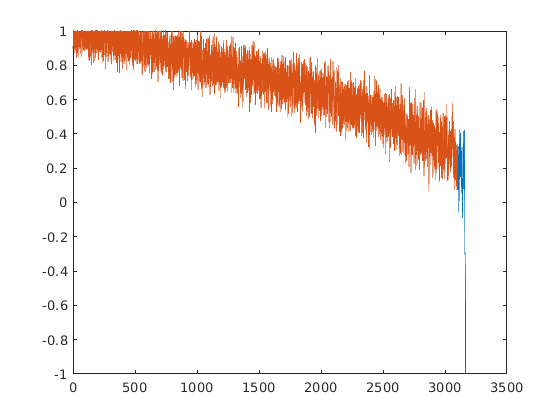

clf
plot(finResultsFold.sim_1(:,1),finResultsFold.sim_1(:,2))
hold on
plot(finResultsFold.sim_1(1:310000,1),finResultsFold.sim_1(1:310000,2))
ylim([-1,1])

[imf,residual,info] = emd(df_fold(:,3),'Interpolation','pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        3     |     0.058592   |  SiftMaxRelativeTolerance
      2      |        3     |      0.10602   |  SiftMaxRelativeTolerance
      3      |        3     |       0.1113   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10497   |  SiftMaxRelativeTolerance
      5      |        2     |      0.18775   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11595   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088254   |  SiftMaxRelativeTolerance
      8      |        2     |     0.080192   |  SiftMaxRelativeTolerance
      9      |        2     |     0.046576   |  SiftMaxRelativeTolerance
     10      |        2     |     0.061721   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


% Perform ensemble EMD
imf_eemd_fold = eEMD(finResultsFold.sim_1(1:310000,2),0.2,250,10,'pchip');

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030858   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06455   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079411   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092156   |  SiftMaxRelativeTolerance
      5      |        2     |        0.133   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13082   |  SiftMaxRelativeTolerance
      7      |        2     |      0.08391   |  SiftMaxRelativeTolerance
      8      |        2     |     0.066553   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092924   |  SiftMaxRelativeTolerance
     10      |        2     |     0.077573   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1704    0.2175   -0.0193   -0.0214   -0.0017   -0.0273   -0.0109   -0.0152   -0.0038   -0.0022
    0.3103   -0.1499   -0.0695   -0.0302    0.0006   -0.0274   -0.0104   -0.0152   -0.0037   -0.0022
   -0.3257   -0.1895   -0.0987   -0.0384    0.0028   -0.0273   -0.0100   -0.0152   -0.0037   -0.0022
    0.2659    0.0034   -0.0958   -0.0459    0.0049   -0.0271   -0.0095   -0.0153   -0.0036   -0.0022
   -0.2070    0.1658   -0.0700   -0.0528    0.0069   -0.0268   -0.0090   -0.0152   -0.0036   -0.0022
    0.1358    0.1115   -0.0318   -0.0591    0.0088   -0.0264   -0.0086   -0.0152   -0.0035   -0.0022
    0.2123    0.0249    0.0060   -0.0646    0.0106   -0.0259   -0.0081   -0.0152   -0.0035   -0.0022
   -0.1879   -0.0989    0.0328   -0.0692    0.0122   -0.0254   -0.0076   -0.0152   -0.0034   -0.0022
    0.1339   -0.1046    0.0485   -0.0730    0.0137   -0.0247   -0.0072   -0.0152   -0.0033   -0.0022
   -0.1185   -0.0043    0.0610   -0.0757    0.0151   -0.0240   -0.0067   -0.0151   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030738   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064524   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07566   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094998   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12383   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12902   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09478   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073186   |  SiftMaxRelativeTolerance
      9      |        2     |     0.077954   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14581   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1275   -0.0647   -0.0120    0.0359    0.0618    0.0059   -0.0108    0.0185   -0.0053    0.0017
   -0.0938   -0.1275   -0.0235    0.0386    0.0607    0.0052   -0.0106    0.0184   -0.0052    0.0017
    0.0773   -0.0885   -0.0339    0.0413    0.0596    0.0044   -0.0104    0.0183   -0.0052    0.0017
   -0.0654   -0.0072   -0.0430    0.0439    0.0585    0.0037   -0.0103    0.0182   -0.0052    0.0017
    0.0378    0.0707   -0.0500    0.0465    0.0573    0.0029   -0.0101    0.0181   -0.0052    0.0017
   -0.0127    0.1250   -0.0540    0.0489    0.0561    0.0022   -0.0099    0.0180   -0.0051    0.0017
    0.0698    0.0816   -0.0528    0.0501    0.0546    0.0014   -0.0098    0.0179   -0.0051    0.0017
   -0.1395    0.0202   -0.0453    0.0493    0.0524    0.0006   -0.0096    0.0178   -0.0051    0.0016
   -0.0169    0.0012   -0.0327    0.0468    0.0494   -0.0001   -0.0094    0.0177   -0.0051    0.0016
    0.1837   -0.0233   -0.0161    0.0429    0.0458   -0.0009   -0.0093    0.0177   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030815   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062682   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077418   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095248   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12392   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1344   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088648   |  SiftMaxRelativeTolerance
      8      |        2     |     0.094717   |  SiftMaxRelativeTolerance
      9      |        2     |     0.042676   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082254   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1434    0.0245    0.0121    0.0448   -0.0589   -0.0421   -0.0140   -0.0060   -0.0010    0.0067
    0.1965    0.0060   -0.0036    0.0287   -0.0603   -0.0422   -0.0140   -0.0059   -0.0010    0.0067
   -0.1813   -0.0029   -0.0160    0.0079   -0.0616   -0.0423   -0.0141   -0.0059   -0.0009    0.0067
   -0.1492   -0.0114   -0.0173   -0.0145   -0.0629   -0.0424   -0.0141   -0.0058   -0.0009    0.0067
    0.1013    0.0003   -0.0091   -0.0366   -0.0643   -0.0425   -0.0141   -0.0057   -0.0008    0.0067
   -0.0730    0.0045    0.0002   -0.0561   -0.0655   -0.0427   -0.0141   -0.0057   -0.0008    0.0067
    0.0671   -0.0156    0.0184   -0.0724   -0.0667   -0.0428   -0.0141   -0.0056   -0.0007    0.0068
   -0.0968    0.0264    0.0324   -0.0867   -0.0678   -0.0429   -0.0142   -0.0055   -0.0007    0.0068
   -0.1555    0.1070    0.0235   -0.0977   -0.0689   -0.0430   -0.0142   -0.0055   -0.0006    0.0068
    0.1747    0.1362   -0.0045   -0.1035   -0.0698   -0.0431   -0.0142   -0.0054   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030429   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064388   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074041   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090515   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14744   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12363   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087689   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10655   |  SiftMaxRelativeTolerance
      9      |        2     |     0.097442   |  SiftMaxRelativeTolerance
     10      |        2     |     0.060839   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2516   -0.0004   -0.0615    0.0608    0.0071    0.0123    0.0111    0.0112    0.0259    0.0159
   -0.2043    0.0045   -0.0354    0.0394    0.0062    0.0120    0.0108    0.0108    0.0258    0.0159
   -0.1582    0.0103   -0.0078    0.0165    0.0054    0.0117    0.0104    0.0104    0.0257    0.0158
    0.2524    0.0149    0.0196   -0.0068    0.0045    0.0113    0.0101    0.0099    0.0256    0.0158
   -0.2334   -0.0154    0.0457   -0.0294    0.0037    0.0110    0.0097    0.0095    0.0255    0.0158
    0.1880   -0.0171    0.0702   -0.0503    0.0029    0.0106    0.0093    0.0090    0.0254    0.0157
   -0.1468    0.0230    0.0794   -0.0691    0.0021    0.0102    0.0089    0.0086    0.0253    0.0157
    0.1199    0.0313    0.0657   -0.0867    0.0013    0.0098    0.0085    0.0081    0.0252    0.0157
   -0.0970   -0.0132    0.0365   -0.1033    0.0006    0.0094    0.0081    0.0076    0.0251    0.0156
    0.0952   -0.0708   -0.0016   -0.1184   -0.0001    0.0090    0.0076    0.0072    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031616   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065414   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071437   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094023   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13129   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12701   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10418   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091688   |  SiftMaxRelativeTolerance
      9      |        2     |     0.081459   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12256   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1597    0.1892    0.0105    0.0796    0.0218    0.0063   -0.0198   -0.0078    0.0030    0.0026
   -0.1855    0.0268   -0.0855    0.0607    0.0203    0.0061   -0.0193   -0.0079    0.0030    0.0026
   -0.2647   -0.1096   -0.1385    0.0453    0.0189    0.0058   -0.0188   -0.0079    0.0030    0.0026
    0.1724   -0.0245   -0.1215    0.0326    0.0174    0.0055   -0.0183   -0.0079    0.0030    0.0026
   -0.0888    0.0760   -0.0642    0.0209    0.0159    0.0052   -0.0178   -0.0080    0.0030    0.0026
    0.1057   -0.0413    0.0015    0.0109    0.0145    0.0049   -0.0173   -0.0080    0.0030    0.0026
   -0.1488   -0.0792    0.0552    0.0031    0.0130    0.0047   -0.0167   -0.0080    0.0030    0.0026
    0.1416    0.0387    0.0902   -0.0021    0.0115    0.0044   -0.0162   -0.0080    0.0030    0.0026
   -0.1092    0.1137    0.0905   -0.0051    0.0100    0.0041   -0.0157   -0.0080    0.0030    0.0026
    0.1127    0.0730    0.0634   -0.0075    0.0085    0.0038   -0.0152   -0.0079    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031185   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06174   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076457   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09841   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12845   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14248   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094917   |  SiftMaxRelativeTolerance
      8      |        2     |     0.080258   |  SiftMaxRelativeTolerance
      9      |        2     |     0.051021   |  SiftMaxRelativeTolerance
     10      |        2     |     0.062755   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0639    0.0084   -0.0017   -0.0229   -0.0398   -0.0327   -0.0207   -0.0447   -0.0231   -0.0192
   -0.0380   -0.0351    0.0034   -0.0163   -0.0315   -0.0294   -0.0198   -0.0444   -0.0229   -0.0191
    0.0096   -0.0758    0.0010   -0.0069   -0.0196   -0.0260   -0.0189   -0.0440   -0.0226   -0.0191
    0.0764   -0.1058   -0.0047    0.0035   -0.0052   -0.0225   -0.0180   -0.0436   -0.0224   -0.0190
   -0.1039   -0.0362   -0.0048    0.0130    0.0107   -0.0191   -0.0171   -0.0432   -0.0222   -0.0190
    0.1162    0.0828    0.0022    0.0198    0.0270   -0.0156   -0.0162   -0.0428   -0.0220   -0.0189
   -0.0832    0.0565    0.0066    0.0217    0.0426   -0.0122   -0.0152   -0.0423   -0.0218   -0.0189
    0.0764   -0.0490    0.0010    0.0169    0.0566   -0.0088   -0.0143   -0.0419   -0.0216   -0.0188
   -0.1110   -0.0355   -0.0067    0.0066    0.0679   -0.0056   -0.0133   -0.0415   -0.0214   -0.0188
    0.1276    0.0309   -0.0051   -0.0046    0.0754   -0.0024   -0.0124   -0.0411   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031256   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06076   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072661   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10027   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12951   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13914   |  SiftMaxRelativeTolerance
      7      |        2     |     0.096424   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070502   |  SiftMaxRelativeTolerance
      9      |        2     |     0.074038   |  SiftMaxRelativeTolerance
     10      |        2     |      0.05763   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0334    0.2011   -0.0033    0.0468    0.0668   -0.0178   -0.0029   -0.0083    0.0034    0.0062
    0.1546    0.0029   -0.0183    0.0350    0.0625   -0.0176   -0.0028   -0.0081    0.0034    0.0062
   -0.1675   -0.0916   -0.0318    0.0221    0.0583   -0.0174   -0.0028   -0.0080    0.0034    0.0062
    0.0423   -0.1468   -0.0426    0.0084    0.0541   -0.0173   -0.0027   -0.0079    0.0033    0.0062
    0.1687   -0.1844   -0.0495   -0.0059    0.0498   -0.0171   -0.0026   -0.0077    0.0033    0.0062
   -0.1655   -0.1889   -0.0512   -0.0205    0.0456   -0.0169   -0.0026   -0.0076    0.0033    0.0062
    0.1427   -0.1039   -0.0497   -0.0351    0.0415   -0.0167   -0.0025   -0.0075    0.0032    0.0061
   -0.0931   -0.0067   -0.0479   -0.0494    0.0373   -0.0165   -0.0025   -0.0073    0.0032    0.0061
    0.0327    0.0592   -0.0458   -0.0633    0.0332   -0.0163   -0.0024   -0.0072    0.0031    0.0061
   -0.0446    0.1530   -0.0434   -0.0764    0.0292   -0.0162   -0.0023   -0.0071    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031176   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061769   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079655   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10027   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12573   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13631   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10549   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10823   |  SiftMaxRelativeTolerance
      9      |        2     |     0.095407   |  SiftMaxRelativeTolerance
     10      |        2     |     0.093348   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2063    0.0070   -0.0152    0.0376    0.0199    0.0035   -0.0072   -0.0047   -0.0049    0.0062
    0.1610    0.0948   -0.0242    0.0397    0.0199    0.0035   -0.0072   -0.0047   -0.0049    0.0062
   -0.1185    0.0105   -0.0260    0.0414    0.0199    0.0035   -0.0072   -0.0047   -0.0050    0.0062
    0.0887   -0.1021   -0.0186    0.0419    0.0199    0.0035   -0.0072   -0.0047   -0.0050    0.0062
   -0.1443    0.0068   -0.0026    0.0407    0.0199    0.0035   -0.0072   -0.0046   -0.0050    0.0062
    0.2035    0.0998    0.0158    0.0381    0.0199    0.0035   -0.0072   -0.0046   -0.0050    0.0062
   -0.1294    0.0216    0.0293    0.0343    0.0198    0.0035   -0.0072   -0.0046   -0.0050    0.0062
   -0.2006   -0.0594    0.0364    0.0295    0.0197    0.0035   -0.0073   -0.0046   -0.0051    0.0062
    0.1922   -0.0830    0.0362    0.0239    0.0196    0.0035   -0.0073   -0.0046   -0.0051    0.0062
   -0.2020   -0.0129    0.0207    0.0179    0.0194    0.0035   -0.0073   -0.0045   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030848   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064681   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076041   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092186   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13596   |  SiftMaxRelativeTolerance
      6      |        2     |      0.10668   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083634   |  SiftMaxRelativeTolerance
      8      |        2     |     0.068551   |  SiftMaxRelativeTolerance
      9      |        2     |      0.05679   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12307   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0285   -0.1039   -0.2144   -0.0765    0.0080   -0.0448   -0.0679   -0.0299   -0.0479   -0.0289
    0.1238    0.0786   -0.1526   -0.0554    0.0108   -0.0450   -0.0673   -0.0292   -0.0474   -0.0288
    0.1206    0.1937   -0.0977   -0.0342    0.0137   -0.0450   -0.0667   -0.0285   -0.0469   -0.0287
   -0.0936    0.1705   -0.0583   -0.0131    0.0169   -0.0450   -0.0661   -0.0278   -0.0464   -0.0286
    0.0992    0.0589   -0.0328    0.0075    0.0204   -0.0449   -0.0654   -0.0272   -0.0459   -0.0285
   -0.0137   -0.0456   -0.0142    0.0272    0.0240   -0.0447   -0.0647   -0.0265   -0.0455   -0.0284
   -0.1681   -0.0921   -0.0001    0.0459    0.0278   -0.0445   -0.0640   -0.0258   -0.0450   -0.0283
    0.1561   -0.0387    0.0300    0.0631    0.0318   -0.0442   -0.0633   -0.0251   -0.0445   -0.0282
    0.0363    0.0370    0.0819    0.0786    0.0359   -0.0438   -0.0625   -0.0244   -0.0440   -0.0281
   -0.0500    0.0338    0.1356    0.0920    0.0401   -0.0434   -0.0617   -0.0237   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03104   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062461   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075443   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095481   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12909   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1262   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093459   |  SiftMaxRelativeTolerance
      8      |        2     |     0.072381   |  SiftMaxRelativeTolerance
      9      |        2     |     0.049076   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11018   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0790    0.0238    0.0125    0.0762    0.0151   -0.0200   -0.0382   -0.0115   -0.0027   -0.0005
   -0.3276   -0.0077    0.0037    0.0746    0.0151   -0.0196   -0.0378   -0.0114   -0.0027   -0.0004
    0.0051   -0.0243   -0.0043    0.0728    0.0151   -0.0192   -0.0374   -0.0113   -0.0028   -0.0004
    0.0872   -0.0277   -0.0107    0.0708    0.0152   -0.0187   -0.0370   -0.0112   -0.0028   -0.0004
    0.2746   -0.0183   -0.0148    0.0685    0.0153   -0.0183   -0.0365   -0.0111   -0.0028   -0.0004
   -0.2672   -0.0053   -0.0163    0.0660    0.0154   -0.0178   -0.0361   -0.0110   -0.0028   -0.0004
    0.2639    0.0009   -0.0152    0.0628    0.0155   -0.0173   -0.0356   -0.0109   -0.0028   -0.0004
    0.0698    0.0035   -0.0110    0.0580    0.0157   -0.0168   -0.0351   -0.0108   -0.0028   -0.0004
   -0.0816    0.0042   -0.0036    0.0512    0.0159   -0.0163   -0.0346   -0.0107   -0.0028   -0.0004
   -0.1466    0.0032    0.0064    0.0426    0.0162   -0.0158   -0.0340   -0.0106   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030843   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065734   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075283   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091286   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12475   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15019   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094425   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10987   |  SiftMaxRelativeTolerance
      9      |        2     |        0.105   |  SiftMaxRelativeTolerance
     10      |        2     |     0.061024   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0928    0.1615    0.0545   -0.0551   -0.0053   -0.0248   -0.0522   -0.0264   -0.0043   -0.0175
    0.0024    0.0982    0.0134   -0.0399   -0.0010   -0.0240   -0.0514   -0.0261   -0.0042   -0.0175
    0.0947    0.0391   -0.0276   -0.0239    0.0032   -0.0229   -0.0505   -0.0259   -0.0042   -0.0175
   -0.0369   -0.0238   -0.0649   -0.0083    0.0071   -0.0216   -0.0497   -0.0257   -0.0041   -0.0175
   -0.0823   -0.0891   -0.0951    0.0058    0.0108   -0.0200   -0.0488   -0.0255   -0.0041   -0.0175
    0.0941   -0.1447   -0.1148    0.0175    0.0142   -0.0181   -0.0479   -0.0253   -0.0041   -0.0175
   -0.1347   -0.1019   -0.1121    0.0275    0.0172   -0.0161   -0.0470   -0.0251   -0.0040   -0.0175
    0.1522   -0.0043   -0.0856    0.0368    0.0198   -0.0138   -0.0461   -0.0248   -0.0040   -0.0174
    0.0244    0.0301   -0.0473    0.0449    0.0219   -0.0113   -0.0452   -0.0246   -0.0039   -0.0174
   -0.0929    0.0225   -0.0090    0.0514    0.0234   -0.0087   -0.0443   -0.0244   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030879   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063426   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072791   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10294   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12482   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1391   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099034   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078742   |  SiftMaxRelativeTolerance
      9      |        2     |     0.055681   |  SiftMaxRelativeTolerance
     10      |        3     |     0.095255   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1031    0.0068    0.0883   -0.0662    0.0017   -0.0227   -0.0005   -0.0046   -0.0007   -0.0046
    0.1267   -0.0886    0.0807   -0.0720    0.0042   -0.0232   -0.0003   -0.0045   -0.0007   -0.0046
   -0.1533   -0.0860    0.0717   -0.0781    0.0067   -0.0236   -0.0001   -0.0045   -0.0007   -0.0046
   -0.1013   -0.0376    0.0589   -0.0843    0.0092   -0.0240    0.0001   -0.0044   -0.0007   -0.0046
    0.0053    0.0256    0.0412   -0.0905    0.0116   -0.0245    0.0003   -0.0044   -0.0007   -0.0046
    0.1503    0.0786    0.0216   -0.0966    0.0139   -0.0249    0.0005   -0.0043   -0.0007   -0.0046
    0.3357    0.0982    0.0016   -0.1025    0.0162   -0.0254    0.0007   -0.0042   -0.0006   -0.0046
   -0.3353    0.0601   -0.0232   -0.1080    0.0184   -0.0258    0.0009   -0.0042   -0.0006   -0.0046
    0.1021   -0.0128   -0.0536   -0.1129    0.0206   -0.0262    0.0011   -0.0041   -0.0006   -0.0046
    0.2909   -0.0586   -0.0842   -0.1172    0.0226   -0.0267    0.0013   -0.0041   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030956   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064905   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0751   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090963   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13512   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12838   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089481   |  SiftMaxRelativeTolerance
      8      |        2     |     0.090634   |  SiftMaxRelativeTolerance
      9      |        2     |     0.068308   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058357   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2870   -0.0338    0.0286   -0.0001   -0.0076   -0.0484   -0.0246   -0.0003    0.0110   -0.0111
   -0.2801   -0.0577    0.0186    0.0033   -0.0083   -0.0478   -0.0236   -0.0001    0.0110   -0.0110
    0.2682   -0.0441    0.0079    0.0068   -0.0089   -0.0472   -0.0226    0.0001    0.0110   -0.0110
    0.1988   -0.0052   -0.0033    0.0101   -0.0096   -0.0466   -0.0215    0.0003    0.0110   -0.0110
   -0.1245    0.0365   -0.0144    0.0130   -0.0103   -0.0458   -0.0205    0.0005    0.0111   -0.0110
   -0.1877    0.0602   -0.0250    0.0154   -0.0110   -0.0450   -0.0195    0.0008    0.0111   -0.0110
   -0.1301    0.0677   -0.0345    0.0170   -0.0118   -0.0441   -0.0185    0.0010    0.0111   -0.0110
    0.1312    0.0633   -0.0369    0.0176   -0.0126   -0.0432   -0.0174    0.0012    0.0111   -0.0110
   -0.1055    0.0033   -0.0288    0.0173   -0.0134   -0.0422   -0.0164    0.0014    0.0111   -0.0109
    0.0985   -0.0746   -0.0134    0.0162   -0.0143   -0.0412   -0.0154    0.0016    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030447   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065163   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077613   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094523   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1237   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13455   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10515   |  SiftMaxRelativeTolerance
      8      |        2     |      0.13759   |  SiftMaxRelativeTolerance
      9      |        2     |     0.040007   |  SiftMaxRelativeTolerance
     10      |        2     |     0.096925   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0393    0.0089    0.0135    0.0626    0.0288    0.0122   -0.0033   -0.0145   -0.0015    0.0040
   -0.2079   -0.0096    0.0052    0.0613    0.0268    0.0115   -0.0030   -0.0144   -0.0015    0.0040
   -0.0174   -0.0187   -0.0037    0.0595    0.0248    0.0108   -0.0028   -0.0144   -0.0015    0.0040
    0.0526   -0.0215   -0.0119    0.0572    0.0227    0.0101   -0.0026   -0.0144   -0.0015    0.0040
    0.1748   -0.0148   -0.0190    0.0544    0.0205    0.0094   -0.0023   -0.0144   -0.0015    0.0040
   -0.1259   -0.0007   -0.0252    0.0510    0.0184    0.0087   -0.0021   -0.0144   -0.0015    0.0040
   -0.1625    0.0143   -0.0307    0.0472    0.0162    0.0080   -0.0019   -0.0144   -0.0015    0.0040
    0.1038    0.0277   -0.0348    0.0429    0.0140    0.0072   -0.0016   -0.0144   -0.0014    0.0041
    0.1462    0.0361   -0.0358    0.0382    0.0117    0.0065   -0.0014   -0.0144   -0.0014    0.0041
    0.0448    0.0113   -0.0301    0.0332    0.0095    0.0058   -0.0012   -0.0144   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030342   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063156   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074957   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10274   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12487   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1471   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10003   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070857   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15135   |  SiftMaxRelativeTolerance
     10      |        2     |     0.034012   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1897   -0.0873    0.0237    0.0240    0.0543   -0.0038    0.0043   -0.0043    0.0011    0.0072
   -0.1540   -0.1973    0.0196    0.0203    0.0515   -0.0053    0.0045   -0.0043    0.0011    0.0072
    0.1187   -0.1659    0.0163    0.0161    0.0483   -0.0069    0.0047   -0.0043    0.0011    0.0072
   -0.0821   -0.1024    0.0127    0.0115    0.0446   -0.0085    0.0050   -0.0043    0.0011    0.0072
    0.0684   -0.0705    0.0091    0.0066    0.0406   -0.0101    0.0052   -0.0043    0.0011    0.0072
   -0.0659   -0.0336    0.0053    0.0016    0.0364   -0.0116    0.0054   -0.0043    0.0011    0.0072
    0.0674    0.0099    0.0017   -0.0033    0.0319   -0.0133    0.0056   -0.0043    0.0011    0.0072
    0.0533    0.0637   -0.0018   -0.0081    0.0272   -0.0149    0.0059   -0.0042    0.0011    0.0072
   -0.1020    0.1355   -0.0050   -0.0126    0.0224   -0.0165    0.0061   -0.0042    0.0011    0.0072
    0.1273    0.1580   -0.0077   -0.0166    0.0175   -0.0181    0.0063   -0.0042    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030659   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064063   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075379   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095003   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12119   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12255   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095716   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073473   |  SiftMaxRelativeTolerance
      9      |        2     |     0.085841   |  SiftMaxRelativeTolerance
     10      |        2     |     0.057411   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2348   -0.0915    0.0008    0.0231    0.0127    0.0019    0.0052    0.0106    0.0166    0.0112
   -0.0033   -0.0928   -0.0029    0.0130    0.0095    0.0013    0.0050    0.0106    0.0166    0.0112
    0.2364   -0.0910   -0.0045   -0.0013    0.0065    0.0007    0.0049    0.0106    0.0165    0.0112
    0.1584   -0.0969   -0.0029   -0.0198    0.0036    0.0001    0.0047    0.0106    0.0165    0.0111
   -0.2063   -0.1106    0.0029   -0.0422    0.0008   -0.0006    0.0045    0.0106    0.0165    0.0111
    0.1561   -0.0144    0.0107   -0.0669   -0.0019   -0.0013    0.0043    0.0106    0.0165    0.0111
   -0.1143    0.0965    0.0185   -0.0923   -0.0044   -0.0020    0.0041    0.0106    0.0165    0.0111
    0.1225    0.0588    0.0145   -0.1155   -0.0068   -0.0028    0.0040    0.0106    0.0164    0.0111
   -0.1305   -0.0230   -0.0057   -0.1338   -0.0090   -0.0035    0.0038    0.0106    0.0164    0.0111
    0.1271   -0.0487   -0.0307   -0.1462   -0.0111   -0.0043    0.0036    0.0105    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030917   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063242   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074898   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091997   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14026   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1331   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10558   |  SiftMaxRelativeTolerance
      8      |        2     |      0.13014   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073182   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082928   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0923   -0.0483   -0.0283   -0.0563   -0.0145   -0.0674    0.0144   -0.0222   -0.0294   -0.0110
   -0.1272    0.0592   -0.0055   -0.0582   -0.0124   -0.0675    0.0156   -0.0221   -0.0293   -0.0110
    0.1446    0.0652    0.0135   -0.0594   -0.0104   -0.0674    0.0169   -0.0221   -0.0292   -0.0109
    0.0968    0.0449    0.0290   -0.0597   -0.0083   -0.0672    0.0181   -0.0220   -0.0291   -0.0109
    0.0500    0.0190    0.0422   -0.0592   -0.0063   -0.0670    0.0193   -0.0219   -0.0291   -0.0108
   -0.1960   -0.0044    0.0522   -0.0580   -0.0043   -0.0666    0.0206   -0.0218   -0.0290   -0.0108
   -0.1936   -0.0218    0.0585   -0.0562   -0.0024   -0.0661    0.0218   -0.0217   -0.0289   -0.0107
    0.0218   -0.0342    0.0603   -0.0537   -0.0005   -0.0654    0.0230   -0.0216   -0.0288   -0.0107
    0.1018   -0.0397    0.0571   -0.0509    0.0014   -0.0647    0.0243   -0.0215   -0.0288   -0.0106
    0.2402   -0.0318    0.0438   -0.0470    0.0031   -0.0639    0.0255   -0.0214   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031138   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062972   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077121   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093576   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13482   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12575   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087417   |  SiftMaxRelativeTolerance
      8      |        2     |     0.072357   |  SiftMaxRelativeTolerance
      9      |        2     |     0.060636   |  SiftMaxRelativeTolerance
     10      |        2     |     0.063327   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0044    0.0223    0.0012    0.0032    0.0062   -0.0662   -0.0098   -0.0095   -0.0085   -0.0042
   -0.0498   -0.0087    0.0112    0.0205    0.0064   -0.0660   -0.0095   -0.0094   -0.0084   -0.0042
   -0.2180   -0.0375    0.0192    0.0385    0.0066   -0.0656   -0.0092   -0.0092   -0.0084   -0.0042
   -0.3107   -0.0588    0.0230    0.0561    0.0066   -0.0652   -0.0089   -0.0091   -0.0083   -0.0042
    0.0144   -0.0409    0.0233    0.0724    0.0065   -0.0647   -0.0086   -0.0089   -0.0083   -0.0042
    0.2578    0.0216    0.0220    0.0861    0.0064   -0.0640   -0.0083   -0.0087   -0.0083   -0.0042
    0.0035    0.0556    0.0198    0.0963    0.0061   -0.0632   -0.0080   -0.0086   -0.0082   -0.0042
   -0.1287    0.0258    0.0104    0.1033    0.0057   -0.0624   -0.0077   -0.0084   -0.0082   -0.0042
    0.0192   -0.0190   -0.0052    0.1078    0.0053   -0.0614   -0.0074   -0.0082   -0.0081   -0.0042
    0.0328   -0.0230   -0.0158    0.1092    0.0047   -0.0604   -0.0071   -0.0081   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031231   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062988   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073392   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089303   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13847   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11525   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092935   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096416   |  SiftMaxRelativeTolerance
      9      |        2     |     0.044581   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12237   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1528   -0.0018   -0.0051   -0.0763    0.0111   -0.0012   -0.0144   -0.0166   -0.0014    0.0004
   -0.0130    0.0035   -0.0004   -0.0749    0.0092   -0.0004   -0.0142   -0.0165   -0.0014    0.0004
    0.1564    0.0113    0.0045   -0.0729    0.0073    0.0004   -0.0140   -0.0164   -0.0014    0.0004
    0.1395    0.0229    0.0090   -0.0703    0.0054    0.0012   -0.0137   -0.0164   -0.0013    0.0004
   -0.1680    0.0443    0.0125   -0.0671    0.0034    0.0019   -0.0134   -0.0163   -0.0013    0.0004
    0.0630    0.0897    0.0146   -0.0635    0.0015    0.0027   -0.0131   -0.0162   -0.0013    0.0004
    0.1170    0.1364    0.0145   -0.0593   -0.0004    0.0034   -0.0128   -0.0161   -0.0012    0.0004
   -0.0598    0.0939    0.0115   -0.0546   -0.0023    0.0041   -0.0124   -0.0160   -0.0012    0.0004
    0.0490   -0.0182    0.0050   -0.0488   -0.0042    0.0047   -0.0120   -0.0159   -0.0012    0.0004
   -0.0866   -0.0939   -0.0050   -0.0414   -0.0060    0.0054   -0.0116   -0.0158   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03096   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062616   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075425   |  SiftMaxRelativeTolerance
      4      |        2     |      0.08752   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12975   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12627   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11056   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10066   |  SiftMaxRelativeTolerance
      9      |        2     |     0.086285   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12141   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0888    0.0862    0.0127    0.0383    0.0420   -0.0120   -0.0195    0.0122   -0.0041   -0.0094
   -0.1694   -0.0596    0.0022    0.0434    0.0406   -0.0121   -0.0192    0.0121   -0.0040   -0.0093
   -0.0278   -0.1784   -0.0077    0.0487    0.0391   -0.0122   -0.0189    0.0121   -0.0040   -0.0093
    0.1227   -0.2427   -0.0161    0.0535    0.0376   -0.0123   -0.0187    0.0120   -0.0039   -0.0093
   -0.1279   -0.2362   -0.0198    0.0576    0.0361   -0.0124   -0.0184    0.0120   -0.0039   -0.0093
    0.1589   -0.2112   -0.0161    0.0592    0.0346   -0.0126   -0.0181    0.0119   -0.0039   -0.0093
   -0.2033   -0.1128   -0.0057    0.0577    0.0326   -0.0127   -0.0178    0.0118   -0.0038   -0.0093
   -0.0410    0.0693    0.0091    0.0542    0.0298   -0.0128   -0.0175    0.0118   -0.0038   -0.0093
    0.2359    0.1937    0.0259    0.0491    0.0262   -0.0129   -0.0172    0.0117   -0.0038   -0.0093
   -0.1582    0.0308    0.0317    0.0406    0.0218   -0.0130   -0.0169    0.0117   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030907   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062869   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077414   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097908   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12165   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14762   |  SiftMaxRelativeTolerance
      7      |        2     |     0.080787   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12099   |  SiftMaxRelativeTolerance
      9      |        2     |     0.057434   |  SiftMaxRelativeTolerance
     10      |        2     |      0.07168   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2035    0.0009    0.0070    0.0415    0.0182   -0.0142   -0.0396   -0.0088   -0.0003    0.0026
   -0.2015   -0.0054    0.0007    0.0351    0.0152   -0.0143   -0.0395   -0.0087   -0.0003    0.0026
    0.1954    0.0042   -0.0062    0.0257    0.0118   -0.0145   -0.0393   -0.0087   -0.0003    0.0026
    0.0593    0.0066   -0.0116    0.0146    0.0081   -0.0146   -0.0392   -0.0086   -0.0004    0.0026
   -0.1646   -0.0023   -0.0142    0.0030    0.0042   -0.0148   -0.0390   -0.0085   -0.0004    0.0027
    0.1563   -0.0038   -0.0097   -0.0092    0.0001   -0.0150   -0.0388   -0.0084   -0.0004    0.0027
   -0.1557    0.0021    0.0032   -0.0212   -0.0041   -0.0151   -0.0387   -0.0083   -0.0005    0.0027
    0.1616   -0.0046    0.0238   -0.0348   -0.0083   -0.0153   -0.0385   -0.0082   -0.0005    0.0027
   -0.1837    0.0218    0.0199   -0.0484   -0.0125   -0.0154   -0.0383   -0.0081   -0.0005    0.0027
    0.2120    0.0340   -0.0117   -0.0563   -0.0166   -0.0156   -0.0382   -0.0080   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031308   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062539   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076956   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097605   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12423   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1283   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10249   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096371   |  SiftMaxRelativeTolerance
      9      |        2     |     0.075891   |  SiftMaxRelativeTolerance
     10      |        2     |     0.048947   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0227    0.1790   -0.0466   -0.0512    0.0330   -0.0314   -0.0119    0.0060    0.0049    0.0117
    0.0917   -0.0393   -0.0636   -0.0473    0.0332   -0.0314   -0.0118    0.0059    0.0048    0.0116
   -0.0835   -0.1719   -0.0803   -0.0433    0.0333   -0.0314   -0.0117    0.0059    0.0048    0.0116
    0.0719   -0.1777   -0.0945   -0.0393    0.0333   -0.0314   -0.0116    0.0058    0.0048    0.0116
   -0.0998   -0.0253   -0.1024   -0.0354    0.0333   -0.0314   -0.0115    0.0058    0.0048    0.0116
    0.0985    0.1231   -0.1028   -0.0306    0.0332   -0.0314   -0.0114    0.0057    0.0048    0.0116
    0.0251    0.1611   -0.0971   -0.0241    0.0331   -0.0314   -0.0114    0.0057    0.0048    0.0115
   -0.0097    0.1553   -0.0899   -0.0162    0.0328   -0.0313   -0.0113    0.0056    0.0048    0.0115
    0.0623    0.0611   -0.0853   -0.0073    0.0325   -0.0312   -0.0112    0.0056    0.0048    0.0115
   -0.0868   -0.0528   -0.0825    0.0022    0.0321   -0.0311   -0.0111    0.0055    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031211   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062283   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074696   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094281   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14513   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13145   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092173   |  SiftMaxRelativeTolerance
      8      |        2     |     0.050029   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12421   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15133   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1101    0.0411    0.0327    0.0469   -0.0009   -0.0128    0.0054    0.0116    0.0035   -0.0077
   -0.0791   -0.0603    0.0378    0.0397   -0.0024   -0.0129    0.0055    0.0115    0.0035   -0.0077
    0.0853   -0.0850    0.0423    0.0323   -0.0039   -0.0129    0.0055    0.0115    0.0035   -0.0077
    0.0077   -0.0424    0.0446    0.0246   -0.0055   -0.0130    0.0056    0.0114    0.0036   -0.0077
   -0.1421    0.0406    0.0439    0.0167   -0.0070   -0.0131    0.0056    0.0113    0.0036   -0.0076
    0.1597    0.0852    0.0409    0.0088   -0.0086   -0.0132    0.0057    0.0112    0.0036   -0.0076
   -0.1580    0.0477    0.0325    0.0008   -0.0101   -0.0132    0.0057    0.0112    0.0037   -0.0076
    0.1611   -0.0197    0.0175   -0.0070   -0.0116   -0.0133    0.0058    0.0111    0.0037   -0.0076
    0.1190   -0.0673   -0.0006   -0.0146   -0.0130   -0.0134    0.0058    0.0110    0.0037   -0.0076
   -0.1944   -0.0763   -0.0182   -0.0220   -0.0144   -0.0134    0.0059    0.0110    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031029   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062856   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07451   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097204   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1363   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13397   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1069   |  SiftMaxRelativeTolerance
      8      |        2     |     0.079977   |  SiftMaxRelativeTolerance
      9      |        2     |     0.074803   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11209   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0209   -0.0209   -0.0006   -0.0655    0.0207   -0.0073   -0.0064    0.0125    0.0013    0.0047
    0.1907    0.0054    0.0094   -0.0736    0.0195   -0.0075   -0.0065    0.0126    0.0013    0.0047
   -0.0032    0.0228    0.0214   -0.0822    0.0184   -0.0076   -0.0065    0.0126    0.0013    0.0047
   -0.1713    0.0313    0.0351   -0.0910    0.0172   -0.0077   -0.0065    0.0126    0.0013    0.0047
    0.1562    0.0350    0.0477   -0.0996    0.0161   -0.0079   -0.0065    0.0127    0.0013    0.0046
   -0.1189   -0.0166    0.0557   -0.1080    0.0150   -0.0080   -0.0066    0.0127    0.0013    0.0046
    0.0825   -0.0469    0.0602   -0.1166    0.0139   -0.0082   -0.0066    0.0127    0.0013    0.0046
   -0.1058    0.0605    0.0388   -0.1251    0.0128   -0.0083   -0.0066    0.0128    0.0013    0.0046
    0.1755    0.0444   -0.0096   -0.1330    0.0118   -0.0084   -0.0066    0.0128    0.0013    0.0046
   -0.2100   -0.0880   -0.0538   -0.1402    0.0107   -0.0086   -0.0067    0.0128    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031025   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0628   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073115   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093906   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14182   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14467   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11899   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1126   |  SiftMaxRelativeTolerance
      9      |        2     |     0.049779   |  SiftMaxRelativeTolerance
     10      |        2     |      0.16845   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2691    0.0141   -0.1147   -0.0080    0.0595   -0.0171   -0.0095   -0.0105   -0.0071   -0.0137
    0.2589    0.0486   -0.1136    0.0039    0.0561   -0.0166   -0.0091   -0.0104   -0.0070   -0.0136
   -0.2325    0.0153   -0.1056    0.0158    0.0526   -0.0160   -0.0087   -0.0104   -0.0070   -0.0135
   -0.1838   -0.0385   -0.0881    0.0277    0.0490   -0.0154   -0.0083   -0.0104   -0.0069   -0.0135
    0.1495   -0.0568   -0.0623    0.0396    0.0453   -0.0148   -0.0080   -0.0103   -0.0068   -0.0134
   -0.1647   -0.0022   -0.0214    0.0511    0.0416   -0.0141   -0.0076   -0.0103   -0.0068   -0.0133
    0.2210    0.0317    0.0317    0.0623    0.0379   -0.0135   -0.0072   -0.0102   -0.0067   -0.0133
   -0.2018    0.0073    0.0831    0.0729    0.0342   -0.0127   -0.0068   -0.0102   -0.0066   -0.0132
   -0.2876   -0.0046    0.1196    0.0830    0.0304   -0.0120   -0.0064   -0.0101   -0.0066   -0.0132
   -0.4122    0.0119    0.1326    0.0922    0.0267   -0.0112   -0.0060   -0.0101   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031275   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062187   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074853   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089922   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1321   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14272   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11501   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12029   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078927   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13042   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1469    0.0756    0.0479    0.0219    0.0106   -0.0551   -0.0229   -0.0051   -0.0074    0.0001
    0.1206    0.1114    0.0202    0.0354    0.0115   -0.0554   -0.0228   -0.0050   -0.0074    0.0001
   -0.0945    0.0422   -0.0089    0.0506    0.0125   -0.0557   -0.0228   -0.0049   -0.0073    0.0001
    0.0787   -0.0747   -0.0375    0.0663    0.0134   -0.0560   -0.0227   -0.0048   -0.0073    0.0001
   -0.0927   -0.0976   -0.0612    0.0810    0.0144   -0.0563   -0.0227   -0.0047   -0.0073    0.0001
    0.1310   -0.0543   -0.0619    0.0945    0.0153   -0.0566   -0.0226   -0.0046   -0.0072    0.0001
    0.1356   -0.0092   -0.0343    0.1072    0.0163   -0.0569   -0.0226   -0.0045   -0.0072    0.0001
   -0.1792    0.0475    0.0069    0.1182    0.0172   -0.0572   -0.0226   -0.0043   -0.0072    0.0001
    0.2529    0.0293    0.0449    0.1266    0.0180   -0.0576   -0.0225   -0.0042   -0.0071    0.0001
   -0.3043   -0.0316    0.0625    0.1315    0.0189   -0.0579   -0.0225   -0.0041   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031075   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064776   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071698   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095025   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12082   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15299   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10487   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10187   |  SiftMaxRelativeTolerance
      9      |        2     |     0.056283   |  SiftMaxRelativeTolerance
     10      |        2     |     0.048656   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0219   -0.1047   -0.0321   -0.0174   -0.0674   -0.0363   -0.0143   -0.0473   -0.0294   -0.0168
    0.3270   -0.0089    0.0350    0.0072   -0.0499   -0.0345   -0.0133   -0.0471   -0.0293   -0.0167
    0.2293    0.0465    0.0601    0.0268   -0.0276   -0.0327   -0.0122   -0.0468   -0.0291   -0.0167
   -0.2372    0.0090    0.0463    0.0391   -0.0030   -0.0309   -0.0112   -0.0466   -0.0289   -0.0166
    0.2094   -0.0336    0.0246    0.0424    0.0217   -0.0291   -0.0101   -0.0463   -0.0287   -0.0166
   -0.2348    0.0413   -0.0119    0.0369    0.0442   -0.0273   -0.0091   -0.0460   -0.0285   -0.0166
    0.2920    0.0359   -0.0415    0.0246    0.0625   -0.0255   -0.0081   -0.0457   -0.0283   -0.0165
   -0.2961   -0.0796   -0.0353    0.0112    0.0742   -0.0236   -0.0071   -0.0453   -0.0281   -0.0165
    0.0498   -0.0924   -0.0038    0.0006    0.0812   -0.0218   -0.0061   -0.0450   -0.0279   -0.0165
    0.0582   -0.0127    0.0269   -0.0095    0.0865   -0.0200   -0.0051   -0.0446   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030805   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064503   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074064   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096391   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11976   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13401   |  SiftMaxRelativeTolerance
      7      |        2     |     0.075034   |  SiftMaxRelativeTolerance
      8      |        2     |      0.13132   |  SiftMaxRelativeTolerance
      9      |        2     |     0.069934   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14718   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0152    0.0454    0.0530   -0.0309    0.0322   -0.0523   -0.0515   -0.0062    0.0033    0.0069
   -0.1815    0.0701    0.0321   -0.0201    0.0325   -0.0526   -0.0516   -0.0061    0.0033    0.0068
    0.0737    0.0807    0.0120   -0.0092    0.0328   -0.0529   -0.0516   -0.0061    0.0033    0.0068
    0.1928    0.0733   -0.0072    0.0015    0.0331   -0.0531   -0.0516   -0.0060    0.0034    0.0068
    0.1273    0.0430   -0.0253    0.0115    0.0333   -0.0534   -0.0516   -0.0059    0.0034    0.0068
   -0.0890   -0.0055   -0.0412    0.0205    0.0336   -0.0536   -0.0516   -0.0059    0.0034    0.0068
   -0.1627   -0.0544   -0.0538    0.0281    0.0338   -0.0538   -0.0516   -0.0058    0.0034    0.0068
   -0.0123   -0.0759   -0.0620    0.0338    0.0339   -0.0541   -0.0516   -0.0057    0.0035    0.0068
    0.0475   -0.0738   -0.0560    0.0378    0.0340   -0.0542   -0.0516   -0.0057    0.0035    0.0068
    0.0902   -0.0665   -0.0330    0.0405    0.0338   -0.0543   -0.0516   -0.0056    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031412   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06225   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075155   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092492   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13871   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13065   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11332   |  SiftMaxRelativeTolerance
      8      |        2     |     0.099376   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078642   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10321   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0400   -0.0787   -0.0652    0.0173    0.0468   -0.0029   -0.0188   -0.0029   -0.0296    0.0003
    0.0237    0.0260   -0.0815    0.0194    0.0430   -0.0031   -0.0186   -0.0027   -0.0295    0.0003
   -0.0426    0.0913   -0.0909    0.0215    0.0392   -0.0034   -0.0184   -0.0026   -0.0295    0.0003
    0.0907    0.0193   -0.0876    0.0227    0.0352   -0.0037   -0.0182   -0.0025   -0.0294    0.0003
   -0.1249   -0.1005   -0.0723    0.0221    0.0312   -0.0039   -0.0180   -0.0023   -0.0294    0.0003
    0.1101   -0.0923   -0.0480    0.0198    0.0273   -0.0043   -0.0177   -0.0022   -0.0293    0.0003
   -0.0879   -0.0475   -0.0184    0.0161    0.0236   -0.0046   -0.0174   -0.0021   -0.0293    0.0003
    0.0796   -0.0151    0.0136    0.0113    0.0200   -0.0049   -0.0171   -0.0019   -0.0292    0.0003
   -0.0718    0.0095    0.0452    0.0057    0.0165   -0.0053   -0.0168   -0.0018   -0.0292    0.0003
    0.0354    0.0511    0.0735   -0.0005    0.0132   -0.0056   -0.0165   -0.0017   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031147   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064757   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074952   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10134   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1341   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11268   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11928   |  SiftMaxRelativeTolerance
      8      |        2     |     0.090436   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06379   |  SiftMaxRelativeTolerance
     10      |        2     |     0.091618   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1100   -0.0724   -0.0467   -0.0231   -0.0098   -0.0172   -0.0365   -0.0090   -0.0055   -0.0028
    0.0780   -0.0683   -0.0215   -0.0244   -0.0032   -0.0170   -0.0355   -0.0087   -0.0054   -0.0028
    0.1177   -0.0608    0.0029   -0.0245    0.0036   -0.0168   -0.0346   -0.0084   -0.0054   -0.0028
   -0.0320   -0.0184    0.0250   -0.0236    0.0106   -0.0165   -0.0336   -0.0082   -0.0054   -0.0028
   -0.1821    0.0598    0.0433   -0.0221    0.0177   -0.0162   -0.0327   -0.0079   -0.0053   -0.0028
    0.1178    0.1133    0.0564   -0.0203    0.0246   -0.0159   -0.0317   -0.0076   -0.0053   -0.0028
    0.2680    0.1084    0.0575   -0.0178    0.0314   -0.0155   -0.0307   -0.0073   -0.0053   -0.0028
   -0.2542    0.0284    0.0352   -0.0129    0.0377   -0.0151   -0.0297   -0.0071   -0.0052   -0.0028
    0.0772   -0.0543   -0.0086   -0.0049    0.0436   -0.0148   -0.0286   -0.0068   -0.0052   -0.0028
    0.1385   -0.0534   -0.0605    0.0051    0.0489   -0.0144   -0.0276   -0.0065   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031709   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064298   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075799   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09246   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12034   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12678   |  SiftMaxRelativeTolerance
      7      |        2     |     0.085469   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069432   |  SiftMaxRelativeTolerance
      9      |        2     |     0.049727   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12856   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1344    0.0216    0.0652   -0.0154   -0.0096   -0.0154   -0.0029   -0.0049   -0.0026   -0.0004
   -0.0697    0.0001    0.0432   -0.0097   -0.0107   -0.0154   -0.0027   -0.0049   -0.0026   -0.0004
    0.2966   -0.0158    0.0169   -0.0040   -0.0119   -0.0155   -0.0026   -0.0049   -0.0025   -0.0004
    0.1440   -0.0246   -0.0102    0.0018   -0.0131   -0.0156   -0.0024   -0.0049   -0.0025   -0.0004
    0.0829   -0.0282   -0.0348    0.0074   -0.0142   -0.0157   -0.0023   -0.0049   -0.0025   -0.0004
   -0.3080   -0.0258   -0.0536    0.0129   -0.0154   -0.0157   -0.0021   -0.0049   -0.0024   -0.0004
   -0.1528   -0.0109   -0.0674    0.0181   -0.0166   -0.0158   -0.0020   -0.0049   -0.0024   -0.0004
    0.2859    0.0164   -0.0792    0.0229   -0.0177   -0.0159   -0.0018   -0.0049   -0.0023   -0.0003
    0.1138    0.0361   -0.0880    0.0273   -0.0188   -0.0160   -0.0017   -0.0049   -0.0023   -0.0003
    0.0957    0.0369   -0.0944    0.0310   -0.0198   -0.0160   -0.0015   -0.0048   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031462   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061849   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073915   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088822   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13649   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14921   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095848   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069997   |  SiftMaxRelativeTolerance
      9      |        2     |     0.068019   |  SiftMaxRelativeTolerance
     10      |        2     |     0.092084   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1518    0.1443   -0.0517   -0.0362    0.0486   -0.0326   -0.0501    0.0221    0.0040   -0.0004
   -0.1606    0.0086   -0.0709   -0.0342    0.0462   -0.0325   -0.0494    0.0220    0.0040   -0.0004
   -0.2006   -0.0930   -0.0872   -0.0321    0.0437   -0.0323   -0.0487    0.0220    0.0040   -0.0003
    0.1986   -0.1179   -0.0974   -0.0301    0.0412   -0.0321   -0.0480    0.0219    0.0040   -0.0003
   -0.0084   -0.0650   -0.0860   -0.0276    0.0386   -0.0318   -0.0473    0.0219    0.0039   -0.0003
   -0.2342    0.0144   -0.0502   -0.0246    0.0360   -0.0316   -0.0466    0.0219    0.0039   -0.0003
    0.2269    0.0711   -0.0049   -0.0209    0.0334   -0.0313   -0.0459    0.0218    0.0039   -0.0003
   -0.1496    0.0003    0.0392   -0.0168    0.0308   -0.0309   -0.0451    0.0218    0.0039   -0.0003
    0.0693   -0.0451    0.0675   -0.0122    0.0281   -0.0306   -0.0444    0.0217    0.0038   -0.0003
   -0.0614    0.0315    0.0801   -0.0073    0.0254   -0.0302   -0.0437    0.0217    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03113   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063111   |  SiftMaxRelativeTolerance
      3      |        2     |     0.080391   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093765   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13289   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13439   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083588   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085937   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14293   |  SiftMaxRelativeTolerance
     10      |        2     |     0.041463   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2867    0.1124    0.0565    0.0224    0.0540   -0.0510    0.0021   -0.0212    0.0080   -0.0035
   -0.3686    0.0250   -0.0315    0.0147    0.0509   -0.0503    0.0025   -0.0211    0.0080   -0.0035
   -0.3645   -0.0582   -0.0812    0.0076    0.0478   -0.0496    0.0030   -0.0211    0.0080   -0.0035
    0.2955   -0.0117   -0.0895    0.0015    0.0446   -0.0489    0.0034   -0.0210    0.0079   -0.0034
   -0.2279    0.0407   -0.0799   -0.0040    0.0414   -0.0481    0.0038   -0.0209    0.0079   -0.0034
    0.1066   -0.0096   -0.0612   -0.0092    0.0382   -0.0474    0.0042   -0.0208    0.0079   -0.0034
    0.1955   -0.0351   -0.0458   -0.0140    0.0350   -0.0466    0.0046   -0.0207    0.0079   -0.0034
    0.0399   -0.0324   -0.0339   -0.0183    0.0317   -0.0457    0.0050   -0.0207    0.0079   -0.0034
   -0.2045   -0.0182   -0.0222   -0.0222    0.0285   -0.0449    0.0054   -0.0206    0.0079   -0.0034
    0.2183   -0.0042   -0.0109   -0.0256    0.0253   -0.0440    0.0059   -0.0205    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030617   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063369   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076381   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091254   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13046   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13595   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11863   |  SiftMaxRelativeTolerance
      8      |        2     |     0.099194   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065545   |  SiftMaxRelativeTolerance
     10      |        2     |     0.096349   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2369   -0.0420   -0.1490   -0.0692   -0.0780   -0.0461   -0.0850   -0.0469   -0.0376   -0.0151
    0.3104    0.0096   -0.0833   -0.0575   -0.0737   -0.0446   -0.0841   -0.0462   -0.0375   -0.0151
    0.3969    0.0437    0.0016   -0.0460   -0.0690   -0.0430   -0.0832   -0.0456   -0.0373   -0.0151
    0.3906    0.0620    0.0889   -0.0349   -0.0640   -0.0415   -0.0822   -0.0449   -0.0372   -0.0151
    0.3708    0.0662    0.1616   -0.0243   -0.0586   -0.0398   -0.0812   -0.0443   -0.0370   -0.0150
    0.0630    0.0235    0.2054   -0.0142   -0.0530   -0.0382   -0.0802   -0.0436   -0.0369   -0.0150
   -0.2383   -0.0479    0.2223   -0.0049   -0.0471   -0.0366   -0.0791   -0.0430   -0.0367   -0.0150
    0.1657   -0.0563    0.2291    0.0036   -0.0409   -0.0349   -0.0780   -0.0424   -0.0366   -0.0150
   -0.1291   -0.0284    0.2350    0.0113   -0.0346   -0.0332   -0.0768   -0.0417   -0.0364   -0.0149
    0.1245   -0.0269    0.2396    0.0179   -0.0282   -0.0315   -0.0755   -0.0411   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031188   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062791   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078181   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092922   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12038   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13097   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1042   |  SiftMaxRelativeTolerance
      8      |        2     |     0.067848   |  SiftMaxRelativeTolerance
      9      |        2     |      0.13782   |  SiftMaxRelativeTolerance
     10      |        2     |      0.09912   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1954    0.0320    0.0122    0.0254    0.0483   -0.0454   -0.0134   -0.0085   -0.0125    0.0041
   -0.1265   -0.0913   -0.0150    0.0160    0.0441   -0.0451   -0.0129   -0.0083   -0.0124    0.0041
    0.0841   -0.0209   -0.0220    0.0066    0.0399   -0.0448   -0.0124   -0.0082   -0.0124    0.0041
   -0.0569    0.0622   -0.0063   -0.0040    0.0356   -0.0445   -0.0118   -0.0081   -0.0124    0.0041
    0.1212   -0.0624    0.0224   -0.0169    0.0314   -0.0442   -0.0113   -0.0079   -0.0123    0.0041
   -0.2806   -0.0332    0.0286   -0.0299    0.0272   -0.0439   -0.0107   -0.0078   -0.0123    0.0040
    0.3910    0.0989    0.0062   -0.0415    0.0231   -0.0436   -0.0102   -0.0077   -0.0122    0.0040
   -0.3644   -0.0333   -0.0239   -0.0498    0.0190   -0.0433   -0.0096   -0.0075   -0.0122    0.0040
    0.2935   -0.1231   -0.0361   -0.0526    0.0150   -0.0430   -0.0091   -0.0074   -0.0122    0.0040
    0.2087   -0.0661   -0.0293   -0.0519    0.0111   -0.0426   -0.0085   -0.0073   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031037   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064167   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074196   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094579   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13243   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13743   |  SiftMaxRelativeTolerance
      7      |        2     |     0.076592   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077395   |  SiftMaxRelativeTolerance
      9      |        3     |     0.021651   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13278   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0098   -0.0093   -0.0365    0.0344    0.0330   -0.0451   -0.0087    0.0050   -0.0030    0.0016
   -0.1765    0.0043   -0.0395    0.0379    0.0301   -0.0440   -0.0086    0.0051   -0.0030    0.0016
   -0.1015    0.0133   -0.0423    0.0413    0.0272   -0.0429   -0.0085    0.0051   -0.0030    0.0016
    0.1819    0.0165   -0.0445    0.0447    0.0243   -0.0418   -0.0083    0.0052   -0.0030    0.0016
    0.0736    0.0104   -0.0446    0.0477    0.0214   -0.0407   -0.0082    0.0053   -0.0029    0.0016
   -0.1813   -0.0013   -0.0416    0.0504    0.0185   -0.0395   -0.0081    0.0054   -0.0029    0.0016
    0.1840   -0.0152   -0.0360    0.0525    0.0156   -0.0383   -0.0079    0.0055   -0.0029    0.0016
   -0.1174   -0.0237   -0.0284    0.0542    0.0127   -0.0371   -0.0078    0.0056   -0.0029    0.0016
   -0.1771   -0.0245   -0.0179    0.0554    0.0098   -0.0359   -0.0077    0.0057   -0.0029    0.0016
   -0.2073   -0.0206   -0.0044    0.0561    0.0069   -0.0346   -0.0075    0.0058   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030533   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064788   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073252   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093383   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12126   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12864   |  SiftMaxRelativeTolerance
      7      |        2     |       0.0768   |  SiftMaxRelativeTolerance
      8      |        2     |     0.071699   |  SiftMaxRelativeTolerance
      9      |        2     |     0.075007   |  SiftMaxRelativeTolerance
     10      |        2     |     0.060681   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1137   -0.0007    0.0143    0.0231    0.0185    0.0025    0.0006   -0.0179   -0.0108    0.0019
   -0.1304    0.0034    0.0140    0.0266    0.0160    0.0021    0.0006   -0.0179   -0.0108    0.0019
   -0.0507    0.0048    0.0140    0.0305    0.0134    0.0016    0.0006   -0.0179   -0.0107    0.0019
    0.0922    0.0012    0.0167    0.0345    0.0108    0.0012    0.0007   -0.0179   -0.0107    0.0019
    0.1382   -0.0104    0.0270    0.0385    0.0082    0.0008    0.0007   -0.0179   -0.0107    0.0019
    0.1590   -0.0266    0.0428    0.0423    0.0056    0.0004    0.0007   -0.0179   -0.0107    0.0019
    0.0388   -0.0234    0.0569    0.0456    0.0031   -0.0001    0.0007   -0.0180   -0.0106    0.0019
   -0.1884    0.0065    0.0653    0.0482    0.0006   -0.0005    0.0008   -0.0180   -0.0106    0.0018
   -0.1293    0.0448    0.0662    0.0501   -0.0019   -0.0009    0.0008   -0.0180   -0.0106    0.0018
    0.1966    0.0748    0.0605    0.0479   -0.0045   -0.0013    0.0008   -0.0180   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030611   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062576   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076157   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094489   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12154   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13569   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098775   |  SiftMaxRelativeTolerance
      8      |        2     |      0.06454   |  SiftMaxRelativeTolerance
      9      |        2     |      0.13715   |  SiftMaxRelativeTolerance
     10      |        2     |     0.069358   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2114   -0.1087    0.0106   -0.0065   -0.0071   -0.0346   -0.0170   -0.0420   -0.0005    0.0008
    0.3078   -0.1316    0.0050   -0.0026   -0.0065   -0.0349   -0.0171   -0.0418   -0.0005    0.0008
    0.1915   -0.1238   -0.0003    0.0013   -0.0058   -0.0352   -0.0172   -0.0417   -0.0005    0.0008
    0.0626   -0.0818   -0.0054    0.0050   -0.0051   -0.0355   -0.0173   -0.0415   -0.0005    0.0008
   -0.3699   -0.0314   -0.0098    0.0083   -0.0045   -0.0357   -0.0174   -0.0413   -0.0005    0.0008
    0.3679    0.0336   -0.0136    0.0110   -0.0038   -0.0360   -0.0175   -0.0412   -0.0005    0.0008
    0.0415    0.1029   -0.0165    0.0130   -0.0030   -0.0362   -0.0176   -0.0410   -0.0005    0.0008
   -0.3060    0.1334   -0.0182    0.0140   -0.0023   -0.0364   -0.0177   -0.0409   -0.0005    0.0008
    0.1109    0.1129   -0.0166    0.0143   -0.0016   -0.0366   -0.0178   -0.0407   -0.0005    0.0008
    0.2262    0.0769   -0.0106    0.0143   -0.0009   -0.0368   -0.0179   -0.0405   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030937   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064275   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075032   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096003   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12803   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13902   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12508   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092759   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093125   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15077   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0462    0.0922    0.0228   -0.0028   -0.0413   -0.0030    0.0066   -0.0064   -0.0041    0.0008
   -0.2638    0.0178    0.0289   -0.0038   -0.0414   -0.0030    0.0066   -0.0065   -0.0041    0.0008
   -0.0592   -0.0433    0.0344   -0.0041   -0.0414   -0.0031    0.0067   -0.0065   -0.0041    0.0008
    0.2287   -0.0869    0.0394   -0.0035   -0.0416   -0.0031    0.0067   -0.0065   -0.0041    0.0008
    0.2051   -0.1156    0.0437   -0.0021   -0.0423   -0.0031    0.0068   -0.0065   -0.0042    0.0008
   -0.1846   -0.1377    0.0473   -0.0003   -0.0433   -0.0032    0.0068   -0.0065   -0.0042    0.0008
    0.1575   -0.0935    0.0526    0.0019   -0.0446   -0.0032    0.0068   -0.0066   -0.0042    0.0008
    0.0831    0.0048    0.0612    0.0041   -0.0461   -0.0033    0.0069   -0.0066   -0.0042    0.0008
   -0.1191    0.0942    0.0712    0.0062   -0.0479   -0.0033    0.0069   -0.0066   -0.0042    0.0008
    0.1365    0.0896    0.0808    0.0076   -0.0498   -0.0033    0.0070   -0.0066   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030977   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06044   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078382   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091504   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11383   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14531   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10411   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11876   |  SiftMaxRelativeTolerance
      9      |        2     |        0.103   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12673   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0114   -0.0305    0.0006    0.0272   -0.0163   -0.0146    0.0025   -0.0064   -0.0098    0.0020
   -0.2810   -0.0956   -0.0011    0.0210   -0.0121   -0.0149    0.0025   -0.0064   -0.0098    0.0020
   -0.1374   -0.1271   -0.0025    0.0146   -0.0077   -0.0152    0.0025   -0.0064   -0.0097    0.0020
    0.1226   -0.1225   -0.0037    0.0079   -0.0032   -0.0155    0.0025   -0.0064   -0.0096    0.0020
    0.1664   -0.0854   -0.0049    0.0012    0.0014   -0.0158    0.0025   -0.0065   -0.0095    0.0020
   -0.1321   -0.0150   -0.0061   -0.0054    0.0059   -0.0161    0.0025   -0.0065   -0.0095    0.0020
    0.1041    0.0757   -0.0070   -0.0118    0.0104   -0.0164    0.0025   -0.0065   -0.0094    0.0020
   -0.0956    0.1221   -0.0076   -0.0179    0.0148   -0.0167    0.0025   -0.0065   -0.0093    0.0020
    0.1209    0.0246   -0.0079   -0.0236    0.0189   -0.0170    0.0025   -0.0065   -0.0092    0.0020
   -0.1392   -0.1041   -0.0083   -0.0287    0.0228   -0.0173    0.0025   -0.0066   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030825   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063952   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076561   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098794   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14144   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12634   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099257   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092911   |  SiftMaxRelativeTolerance
      9      |        2     |     0.053755   |  SiftMaxRelativeTolerance
     10      |        2     |     0.097886   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0061    0.0823   -0.0751    0.0254   -0.0270   -0.0420   -0.0128   -0.0041    0.0018    0.0009
    0.0532   -0.0590   -0.0760    0.0261   -0.0271   -0.0425   -0.0124   -0.0040    0.0018    0.0009
   -0.1139   -0.0848   -0.0751    0.0254   -0.0270   -0.0430   -0.0120   -0.0039    0.0019    0.0009
    0.1383    0.0114   -0.0615    0.0225   -0.0267   -0.0433   -0.0116   -0.0038    0.0019    0.0009
   -0.1101    0.0704   -0.0307    0.0178   -0.0261   -0.0437   -0.0112   -0.0036    0.0019    0.0008
   -0.0311    0.0480    0.0084    0.0117   -0.0254   -0.0439   -0.0109   -0.0035    0.0019    0.0008
    0.1213    0.0130    0.0475    0.0045   -0.0246   -0.0441   -0.0105   -0.0034    0.0020    0.0008
   -0.0290   -0.0195    0.0781   -0.0032   -0.0235   -0.0442   -0.0101   -0.0033    0.0020    0.0008
   -0.1462   -0.0281    0.0928   -0.0111   -0.0223   -0.0443   -0.0097   -0.0032    0.0020    0.0008
    0.1257   -0.0010    0.0746   -0.0183   -0.0211   -0.0443   -0.0093   -0.0031    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030758   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06339   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075154   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094599   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12859   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13464   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10473   |  SiftMaxRelativeTolerance
      8      |        2     |     0.068133   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078967   |  SiftMaxRelativeTolerance
     10      |        2     |     0.071337   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0861    0.0142    0.1041    0.0247   -0.0077   -0.0510   -0.0267   -0.0075   -0.0064    0.0046
   -0.0863    0.0821    0.0353    0.0143   -0.0102   -0.0513   -0.0270   -0.0072   -0.0063    0.0046
    0.0809    0.1458   -0.0297    0.0038   -0.0128   -0.0515   -0.0273   -0.0069   -0.0063    0.0046
   -0.0918    0.1500   -0.0841   -0.0061   -0.0154   -0.0517   -0.0275   -0.0066   -0.0062    0.0047
    0.1652   -0.0415   -0.1262   -0.0149   -0.0180   -0.0519   -0.0278   -0.0063   -0.0062    0.0047
   -0.2197   -0.2012   -0.1451   -0.0221   -0.0205   -0.0521   -0.0281   -0.0061   -0.0061    0.0047
    0.0998   -0.1185   -0.1309   -0.0264   -0.0227   -0.0523   -0.0283   -0.0058   -0.0060    0.0047
    0.1509    0.0146   -0.0894   -0.0274   -0.0246   -0.0526   -0.0286   -0.0055   -0.0060    0.0048
   -0.1452    0.1228   -0.0341   -0.0259   -0.0258   -0.0527   -0.0289   -0.0052   -0.0059    0.0048
    0.1642    0.1205    0.0219   -0.0226   -0.0259   -0.0529   -0.0292   -0.0049   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030474   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064204   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074512   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097226   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12444   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12297   |  SiftMaxRelativeTolerance
      7      |        2     |      0.13211   |  SiftMaxRelativeTolerance
      8      |        2     |      0.06166   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07397   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1009   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1034    0.1024    0.0102   -0.0009    0.0195   -0.0718   -0.0038   -0.0171   -0.0017    0.0141
    0.1327   -0.0324    0.0021    0.0007    0.0232   -0.0740   -0.0039   -0.0170   -0.0017    0.0141
   -0.1481   -0.0803   -0.0060    0.0014    0.0273   -0.0761   -0.0040   -0.0169   -0.0017    0.0141
    0.1595   -0.1081   -0.0137    0.0014    0.0316   -0.0781   -0.0042   -0.0168   -0.0017    0.0142
   -0.1612   -0.1259   -0.0203    0.0010    0.0357   -0.0801   -0.0043   -0.0167   -0.0016    0.0142
    0.1507   -0.1118   -0.0259    0.0003    0.0396   -0.0820   -0.0044   -0.0166   -0.0016    0.0142
   -0.1266   -0.0994   -0.0307   -0.0005    0.0429   -0.0838   -0.0045   -0.0166   -0.0016    0.0142
    0.1122   -0.0691   -0.0344   -0.0012    0.0455   -0.0855   -0.0046   -0.0165   -0.0016    0.0142
   -0.1599    0.0900   -0.0371   -0.0015    0.0473   -0.0870   -0.0047   -0.0164   -0.0016    0.0142
    0.2392    0.1220   -0.0387   -0.0004    0.0476   -0.0884   -0.0048   -0.0163   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031006   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06226   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077317   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098466   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12616   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14303   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10975   |  SiftMaxRelativeTolerance
      8      |        2     |     0.088038   |  SiftMaxRelativeTolerance
      9      |        2     |     0.070677   |  SiftMaxRelativeTolerance
     10      |        2     |     0.060792   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0824    0.0074    0.0141    0.0819   -0.0677   -0.0044   -0.0237   -0.0139   -0.0026   -0.0011
   -0.0945    0.0486    0.0218    0.0802   -0.0669   -0.0040   -0.0237   -0.0139   -0.0026   -0.0011
    0.1135    0.0357    0.0243    0.0784   -0.0661   -0.0035   -0.0236   -0.0138   -0.0025   -0.0011
    0.1161   -0.0036    0.0215    0.0751   -0.0653   -0.0030   -0.0235   -0.0138   -0.0025   -0.0011
    0.0826   -0.0340    0.0162    0.0693   -0.0644   -0.0026   -0.0235   -0.0137   -0.0025   -0.0011
   -0.2123   -0.0290    0.0098    0.0620   -0.0635   -0.0021   -0.0234   -0.0137   -0.0024   -0.0011
   -0.1029    0.0030    0.0032    0.0539   -0.0625   -0.0016   -0.0233   -0.0137   -0.0024   -0.0011
    0.2183    0.0293   -0.0018    0.0459   -0.0615   -0.0011   -0.0232   -0.0136   -0.0024   -0.0011
   -0.1798   -0.0244   -0.0020    0.0390   -0.0605   -0.0007   -0.0232   -0.0136   -0.0023   -0.0011
    0.1231   -0.0437    0.0022    0.0328   -0.0595   -0.0002   -0.0231   -0.0135   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031243   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064724   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074908   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094288   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11764   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11924   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083377   |  SiftMaxRelativeTolerance
      8      |        2     |     0.087298   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079904   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13549   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0748    0.0030    0.0162   -0.0634    0.0194    0.0023   -0.0078   -0.0332   -0.0055    0.0135
    0.0737    0.0085    0.0083   -0.0711    0.0185    0.0023   -0.0075   -0.0330   -0.0055    0.0135
   -0.0653   -0.0000   -0.0003   -0.0780    0.0177    0.0024   -0.0073   -0.0327   -0.0055    0.0135
   -0.0077   -0.0167   -0.0061   -0.0834    0.0168    0.0025   -0.0070   -0.0325   -0.0056    0.0135
    0.0362   -0.0186   -0.0078   -0.0865    0.0158    0.0026   -0.0067   -0.0322   -0.0056    0.0135
   -0.0535    0.0267   -0.0058   -0.0878    0.0149    0.0027   -0.0065   -0.0319   -0.0056    0.0135
    0.1387   -0.0115   -0.0012   -0.0884    0.0140    0.0028   -0.0062   -0.0317   -0.0056    0.0135
   -0.2297   -0.0326    0.0043   -0.0884    0.0131    0.0029   -0.0059   -0.0314   -0.0056    0.0135
    0.2473    0.0379    0.0053   -0.0876    0.0122    0.0030   -0.0056   -0.0311   -0.0057    0.0135
    0.2409    0.0386    0.0013   -0.0863    0.0112    0.0032   -0.0053   -0.0309   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030884   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064834   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076885   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092014   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1254   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13986   |  SiftMaxRelativeTolerance
      7      |        2     |     0.082909   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10891   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06015   |  SiftMaxRelativeTolerance
     10      |        2     |      0.17083   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0132   -0.0167    0.0138   -0.0214   -0.0185    0.0028   -0.0166   -0.0279   -0.0070   -0.0025
   -0.1620   -0.0213    0.0077   -0.0169   -0.0195    0.0022   -0.0161   -0.0277   -0.0069   -0.0025
   -0.0307   -0.0662    0.0016   -0.0122   -0.0204    0.0015   -0.0156   -0.0275   -0.0069   -0.0025
    0.2212   -0.1530   -0.0044   -0.0075   -0.0214    0.0008   -0.0151   -0.0272   -0.0068   -0.0025
    0.1204   -0.2130   -0.0101   -0.0028   -0.0222    0.0002   -0.0146   -0.0270   -0.0068   -0.0025
   -0.3159   -0.2035   -0.0143    0.0017   -0.0230   -0.0005   -0.0140   -0.0268   -0.0067   -0.0025
    0.3270   -0.1476   -0.0160    0.0060   -0.0237   -0.0012   -0.0134   -0.0266   -0.0067   -0.0024
    0.2187   -0.0855   -0.0157    0.0105   -0.0244   -0.0019   -0.0129   -0.0263   -0.0066   -0.0024
   -0.0175   -0.0197   -0.0136    0.0150   -0.0249   -0.0027   -0.0123   -0.0261   -0.0066   -0.0024
   -0.2649    0.0337   -0.0097    0.0194   -0.0254   -0.0034   -0.0117   -0.0258   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03085   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064133   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078472   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092395   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12933   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13818   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087633   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11886   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064856   |  SiftMaxRelativeTolerance
     10      |        2     |      0.17251   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1573   -0.0300   -0.0070   -0.0160   -0.0305    0.0105   -0.0255   -0.0249   -0.0364   -0.0171
   -0.1515    0.0004   -0.0020   -0.0144   -0.0286    0.0108   -0.0256   -0.0242   -0.0362   -0.0170
    0.1429    0.0590    0.0020   -0.0124   -0.0264    0.0111   -0.0257   -0.0236   -0.0360   -0.0170
   -0.0424    0.1484    0.0048   -0.0101   -0.0241    0.0115   -0.0257   -0.0230   -0.0358   -0.0169
   -0.1430    0.2170    0.0063   -0.0077   -0.0217    0.0118   -0.0257   -0.0224   -0.0356   -0.0169
    0.2066    0.1031    0.0065   -0.0051   -0.0191    0.0122   -0.0257   -0.0218   -0.0354   -0.0168
   -0.2814   -0.0470    0.0059   -0.0027   -0.0163    0.0125   -0.0256   -0.0212   -0.0352   -0.0168
   -0.0054   -0.0788    0.0047   -0.0003   -0.0135    0.0129   -0.0255   -0.0205   -0.0349   -0.0168
    0.1251   -0.1064    0.0029    0.0019   -0.0106    0.0132   -0.0254   -0.0199   -0.0347   -0.0167
    0.3703   -0.1333    0.0006    0.0042   -0.0076    0.0135   -0.0252   -0.0193   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031432   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061867   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077745   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093765   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12894   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12906   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098623   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077395   |  SiftMaxRelativeTolerance
      9      |        2     |     0.053722   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10487   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1258   -0.0359    0.0254   -0.0035   -0.0379   -0.0152   -0.0248   -0.0183    0.0116   -0.0065
    0.0992    0.0566    0.0119    0.0005   -0.0381   -0.0155   -0.0246   -0.0181    0.0116   -0.0066
   -0.1034    0.0808   -0.0002    0.0046   -0.0383   -0.0158   -0.0243   -0.0179    0.0115   -0.0066
   -0.0323    0.0366   -0.0101    0.0089   -0.0385   -0.0162   -0.0240   -0.0177    0.0114   -0.0066
    0.1436   -0.0448   -0.0186    0.0130   -0.0387   -0.0165   -0.0237   -0.0175    0.0113   -0.0066
   -0.1524   -0.0917   -0.0252    0.0169   -0.0389   -0.0168   -0.0235   -0.0173    0.0113   -0.0066
    0.1424   -0.0593   -0.0309    0.0205   -0.0391   -0.0172   -0.0232   -0.0171    0.0112   -0.0066
   -0.0391    0.0270   -0.0371    0.0237   -0.0393   -0.0175   -0.0229   -0.0169    0.0111   -0.0066
   -0.1335    0.1066   -0.0433    0.0263   -0.0394   -0.0178   -0.0226   -0.0167    0.0111   -0.0066
    0.1901    0.0492   -0.0463    0.0281   -0.0396   -0.0182   -0.0224   -0.0165    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030205   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062347   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0765   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095217   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12633   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14215   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09405   |  SiftMaxRelativeTolerance
      8      |        2     |     0.076477   |  SiftMaxRelativeTolerance
      9      |        2     |      0.09824   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13591   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1488    0.0290   -0.0118    0.0274   -0.0574   -0.0436   -0.0167   -0.0176   -0.0069    0.0091
    0.1451    0.0355   -0.0118    0.0274   -0.0574   -0.0445   -0.0163   -0.0172   -0.0068    0.0091
   -0.1441    0.0306   -0.0116    0.0273   -0.0574   -0.0453   -0.0159   -0.0168   -0.0067    0.0091
   -0.0730    0.0098   -0.0109    0.0270   -0.0574   -0.0459   -0.0155   -0.0164   -0.0066    0.0091
    0.1527   -0.0163   -0.0097    0.0264   -0.0574   -0.0463   -0.0151   -0.0160   -0.0065    0.0091
   -0.1562   -0.0332   -0.0081    0.0255   -0.0574   -0.0466   -0.0147   -0.0156   -0.0065    0.0092
   -0.1557   -0.0376   -0.0061    0.0245   -0.0575   -0.0467   -0.0143   -0.0152   -0.0064    0.0092
   -0.0979   -0.0305   -0.0041    0.0233   -0.0575   -0.0466   -0.0139   -0.0148   -0.0063    0.0092
    0.0279   -0.0176   -0.0023    0.0218   -0.0575   -0.0464   -0.0135   -0.0144   -0.0062    0.0092
    0.1426   -0.0025   -0.0007    0.0202   -0.0575   -0.0461   -0.0131   -0.0140   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030511   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064033   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076632   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093075   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11779   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15921   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083989   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10042   |  SiftMaxRelativeTolerance
      9      |        2     |     0.041694   |  SiftMaxRelativeTolerance
     10      |        2     |      0.05782   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0918    0.0590   -0.0165    0.0545   -0.0002   -0.0200   -0.0228   -0.0272   -0.0254   -0.0187
    0.1263   -0.0663   -0.0027    0.0553    0.0005   -0.0193   -0.0226   -0.0268   -0.0252   -0.0186
   -0.1250   -0.1089    0.0147    0.0562    0.0012   -0.0185   -0.0223   -0.0264   -0.0250   -0.0185
    0.1073   -0.0589    0.0429    0.0569    0.0019   -0.0177   -0.0221   -0.0259   -0.0248   -0.0185
   -0.0883    0.0433    0.0824    0.0576    0.0026   -0.0168   -0.0218   -0.0255   -0.0246   -0.0184
    0.0789    0.0837    0.1216    0.0582    0.0032   -0.0159   -0.0215   -0.0250   -0.0244   -0.0184
   -0.0654    0.0309    0.1516    0.0586    0.0038   -0.0149   -0.0211   -0.0245   -0.0242   -0.0183
    0.0762   -0.0727    0.1644    0.0589    0.0044   -0.0139   -0.0208   -0.0241   -0.0240   -0.0182
   -0.1517   -0.0605    0.1602    0.0592    0.0050   -0.0129   -0.0204   -0.0236   -0.0238   -0.0182
    0.1077    0.0483    0.1484    0.0595    0.0055   -0.0118   -0.0201   -0.0231   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031207   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063341   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075234   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10052   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13564   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12567   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10038   |  SiftMaxRelativeTolerance
      8      |        2     |     0.094543   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064839   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11084   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0286   -0.0047    0.0469    0.0995   -0.0421   -0.0331   -0.0023   -0.0031    0.0012    0.0031
   -0.0902    0.0430    0.0343    0.1023   -0.0437   -0.0320   -0.0021   -0.0030    0.0012    0.0032
   -0.0202    0.0763    0.0211    0.1048   -0.0453   -0.0309   -0.0020   -0.0030    0.0011    0.0032
    0.0995    0.0888    0.0066    0.1072   -0.0469   -0.0299   -0.0019   -0.0030    0.0011    0.0032
    0.0291    0.0607   -0.0105    0.1092   -0.0485   -0.0288   -0.0018   -0.0030    0.0011    0.0032
   -0.0416    0.0007   -0.0296    0.1109   -0.0501   -0.0277   -0.0017   -0.0029    0.0010    0.0032
   -0.0694   -0.0571   -0.0495    0.1121   -0.0517   -0.0266   -0.0016   -0.0029    0.0010    0.0032
    0.0673   -0.0881   -0.0689    0.1128   -0.0532   -0.0255   -0.0014   -0.0029    0.0010    0.0032
   -0.0770   -0.0822   -0.0864    0.1129   -0.0548   -0.0244   -0.0013   -0.0028    0.0009    0.0032
    0.0909   -0.0595   -0.1011    0.1123   -0.0563   -0.0233   -0.0012   -0.0028    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030935   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061924   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07739   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09127   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12473   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14987   |  SiftMaxRelativeTolerance
      7      |        2     |     0.090042   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096273   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18116   |  SiftMaxRelativeTolerance
     10      |        2     |     0.039356   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0412    0.0362   -0.0157   -0.0771   -0.0406   -0.0655   -0.0320   -0.0203   -0.0073   -0.0060
   -0.0264   -0.0494   -0.0005   -0.0720   -0.0287   -0.0619   -0.0308   -0.0199   -0.0072   -0.0060
    0.0338   -0.0991    0.0105   -0.0633   -0.0167   -0.0583   -0.0296   -0.0195   -0.0071   -0.0060
   -0.0502   -0.0506    0.0139   -0.0520   -0.0046   -0.0547   -0.0284   -0.0191   -0.0070   -0.0060
    0.0569    0.0695    0.0108   -0.0392    0.0072   -0.0510   -0.0272   -0.0187   -0.0069   -0.0060
   -0.0579    0.1214    0.0001   -0.0249    0.0185   -0.0473   -0.0259   -0.0183   -0.0068   -0.0059
    0.1067   -0.0013   -0.0138   -0.0089    0.0293   -0.0437   -0.0247   -0.0178   -0.0067   -0.0059
   -0.1544   -0.1253   -0.0232    0.0079    0.0392   -0.0400   -0.0235   -0.0174   -0.0066   -0.0059
   -0.0140   -0.1191   -0.0232    0.0234    0.0480   -0.0364   -0.0222   -0.0170   -0.0065   -0.0059
    0.0303   -0.0930   -0.0122    0.0361    0.0556   -0.0329   -0.0210   -0.0166   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031213   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0656   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078604   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091503   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12672   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1556   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087208   |  SiftMaxRelativeTolerance
      8      |        2     |     0.088223   |  SiftMaxRelativeTolerance
      9      |        2     |     0.059809   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12228   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0189   -0.1548    0.0401    0.0140    0.0017   -0.0486   -0.0095   -0.0050   -0.0124    0.0101
    0.0824   -0.1291    0.0479    0.0077    0.0025   -0.0492   -0.0093   -0.0049   -0.0124    0.0101
    0.0453   -0.0765    0.0545    0.0015    0.0032   -0.0499   -0.0091   -0.0049   -0.0124    0.0100
   -0.1500    0.0550    0.0592   -0.0045    0.0040   -0.0505   -0.0089   -0.0048   -0.0124    0.0100
    0.1829    0.1436    0.0617   -0.0103    0.0047   -0.0512   -0.0087   -0.0047   -0.0123    0.0100
   -0.1810    0.0976    0.0534   -0.0160    0.0055   -0.0519   -0.0085   -0.0046   -0.0123    0.0100
   -0.0883    0.0196    0.0303   -0.0214    0.0062   -0.0525   -0.0083   -0.0045   -0.0123    0.0100
    0.0032   -0.0514   -0.0012   -0.0264    0.0069   -0.0532   -0.0081   -0.0044   -0.0123    0.0099
    0.1134   -0.0865   -0.0351   -0.0309    0.0077   -0.0538   -0.0079   -0.0043   -0.0122    0.0099
   -0.0024   -0.0593   -0.0584   -0.0346    0.0084   -0.0545   -0.0077   -0.0042   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030759   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063991   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077515   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091847   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12802   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15153   |  SiftMaxRelativeTolerance
      7      |        2     |     0.090121   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081717   |  SiftMaxRelativeTolerance
      9      |        2     |     0.050671   |  SiftMaxRelativeTolerance
     10      |        2     |     0.093031   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0255   -0.0451    0.0894   -0.0093   -0.0231   -0.0204   -0.0057   -0.0178   -0.0030   -0.0079
    0.0250   -0.0170    0.0698   -0.0045   -0.0219   -0.0197   -0.0054   -0.0177   -0.0030   -0.0079
   -0.0375    0.0228    0.0492   -0.0000   -0.0203   -0.0189   -0.0051   -0.0175   -0.0030   -0.0079
   -0.0290    0.0420    0.0287    0.0042   -0.0185   -0.0182   -0.0048   -0.0173   -0.0029   -0.0079
    0.0481    0.0207    0.0048    0.0079   -0.0164   -0.0174   -0.0044   -0.0172   -0.0029   -0.0079
    0.1742   -0.0173   -0.0235    0.0110   -0.0143   -0.0166   -0.0041   -0.0170   -0.0029   -0.0079
   -0.1870   -0.0316   -0.0515    0.0135   -0.0120   -0.0159   -0.0038   -0.0168   -0.0028   -0.0079
    0.0021   -0.0017   -0.0772    0.0152   -0.0098   -0.0151   -0.0035   -0.0167   -0.0028   -0.0079
    0.1666    0.0331   -0.0971    0.0160   -0.0076   -0.0143   -0.0032   -0.0165   -0.0028   -0.0079
   -0.1570    0.0322   -0.1026    0.0157   -0.0055   -0.0135   -0.0028   -0.0163   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030967   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062846   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075085   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099923   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11687   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14825   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092259   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081812   |  SiftMaxRelativeTolerance
      9      |        2     |     0.077603   |  SiftMaxRelativeTolerance
     10      |        2     |     0.062265   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0722   -0.0582   -0.0410   -0.0479   -0.0014   -0.0055    0.0002   -0.0275   -0.0349    0.0059
   -0.1402    0.1196   -0.0045   -0.0390   -0.0007   -0.0050   -0.0003   -0.0269   -0.0349    0.0059
    0.1358    0.2190    0.0234   -0.0298    0.0000   -0.0045   -0.0009   -0.0262   -0.0348    0.0059
   -0.1090    0.1791    0.0426   -0.0204    0.0007   -0.0039   -0.0014   -0.0256   -0.0347    0.0059
    0.0947    0.0562    0.0554   -0.0112    0.0013   -0.0033   -0.0020   -0.0249   -0.0347    0.0059
    0.0152   -0.0508    0.0613   -0.0026    0.0019   -0.0027   -0.0025   -0.0242   -0.0346    0.0059
   -0.1191   -0.1162    0.0595    0.0053    0.0024   -0.0021   -0.0030   -0.0235   -0.0346    0.0059
    0.0178   -0.1261    0.0489    0.0126    0.0028   -0.0015   -0.0035   -0.0228   -0.0345    0.0059
    0.1476   -0.1176    0.0337    0.0195    0.0032   -0.0009   -0.0040   -0.0221   -0.0344    0.0059
   -0.0560   -0.0403    0.0198    0.0261    0.0035   -0.0002   -0.0044   -0.0213   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030583   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062068   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076675   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099094   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13085   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11769   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11005   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10182   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1535   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11096   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2187   -0.1277   -0.0580   -0.0045   -0.0196   -0.0719    0.0176   -0.0157   -0.0244   -0.0109
    0.4617    0.0107   -0.0017    0.0039   -0.0180   -0.0701    0.0183   -0.0156   -0.0244   -0.0109
    0.3187    0.0740    0.0438    0.0114   -0.0153   -0.0682    0.0190   -0.0155   -0.0243   -0.0109
   -0.1755    0.0773    0.0677    0.0178   -0.0119   -0.0662    0.0198   -0.0154   -0.0243   -0.0108
   -0.1550    0.0210    0.0751    0.0227   -0.0078   -0.0641    0.0205   -0.0153   -0.0243   -0.0108
   -0.0411   -0.0525    0.0778    0.0260   -0.0033   -0.0620    0.0212   -0.0152   -0.0243   -0.0108
    0.0514   -0.0716    0.0747    0.0275    0.0015   -0.0598    0.0219   -0.0151   -0.0242   -0.0107
   -0.0609   -0.0103    0.0657    0.0274    0.0065   -0.0576    0.0227   -0.0150   -0.0242   -0.0107
    0.0927    0.0522    0.0523    0.0260    0.0114   -0.0553    0.0234   -0.0149   -0.0242   -0.0107
    0.0514    0.0717    0.0361    0.0235    0.0162   -0.0531    0.0241   -0.0148   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031106   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061337   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077196   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096403   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12183   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16879   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10777   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11333   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078002   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075041   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0379   -0.0803    0.0961    0.0274   -0.0176   -0.0131    0.0218   -0.0183    0.0017   -0.0005
   -0.0897    0.0684    0.1027    0.0277   -0.0181   -0.0126    0.0216   -0.0182    0.0018   -0.0005
    0.0999    0.1471    0.1083    0.0280   -0.0187   -0.0121    0.0213   -0.0181    0.0019   -0.0005
   -0.0919    0.1128    0.1063    0.0281   -0.0192   -0.0115    0.0211   -0.0180    0.0020   -0.0005
    0.1045   -0.0368    0.0943    0.0280   -0.0198   -0.0110    0.0208   -0.0179    0.0021   -0.0005
   -0.1514   -0.1225    0.0760    0.0275   -0.0204   -0.0104    0.0206   -0.0178    0.0022   -0.0005
   -0.1783   -0.0599    0.0547    0.0269   -0.0210   -0.0098    0.0203   -0.0177    0.0022   -0.0004
    0.1390    0.0793    0.0350    0.0260   -0.0218   -0.0092    0.0201   -0.0176    0.0023   -0.0004
   -0.0733    0.0982    0.0221    0.0250   -0.0226   -0.0086    0.0198   -0.0175    0.0024   -0.0004
    0.0777   -0.0324    0.0151    0.0238   -0.0234   -0.0080    0.0195   -0.0174    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031084   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06222   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075294   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096923   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11689   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13552   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11462   |  SiftMaxRelativeTolerance
      8      |        2     |     0.058717   |  SiftMaxRelativeTolerance
      9      |        2     |     0.088111   |  SiftMaxRelativeTolerance
     10      |        2     |     0.049747   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1008    0.0549    0.0545    0.0081    0.0437    0.0150   -0.0077    0.0227    0.0054    0.0031
    0.1459   -0.1116    0.0010    0.0021    0.0416    0.0125   -0.0081    0.0226    0.0054    0.0031
   -0.1514   -0.1517   -0.0654   -0.0031    0.0390    0.0101   -0.0084    0.0226    0.0054    0.0031
   -0.0278   -0.1500   -0.1320   -0.0074    0.0360    0.0076   -0.0088    0.0225    0.0054    0.0031
    0.1497   -0.1303   -0.1837   -0.0108    0.0327    0.0052   -0.0092    0.0225    0.0054    0.0031
   -0.1518   -0.1008   -0.2065   -0.0131    0.0292    0.0027   -0.0096    0.0224    0.0054    0.0031
    0.1571   -0.0473   -0.2042   -0.0142    0.0256    0.0003   -0.0100    0.0224    0.0054    0.0030
   -0.1862    0.0530   -0.1893   -0.0143    0.0218   -0.0022   -0.0104    0.0223    0.0054    0.0030
    0.2208    0.0989   -0.1631   -0.0134    0.0181   -0.0046   -0.0107    0.0223    0.0053    0.0030
    0.0913    0.0617   -0.1293   -0.0119    0.0145   -0.0070   -0.0111    0.0222    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031265   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063237   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075654   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091185   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12191   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14918   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09926   |  SiftMaxRelativeTolerance
      8      |        2     |     0.095937   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12077   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075986   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2578    0.0816   -0.0550   -0.0067   -0.0439   -0.0163   -0.0155   -0.0067    0.0095   -0.0106
    0.0928    0.0850   -0.0405   -0.0127   -0.0445   -0.0166   -0.0151   -0.0067    0.0095   -0.0106
    0.2581    0.0861   -0.0240   -0.0187   -0.0452   -0.0169   -0.0147   -0.0067    0.0095   -0.0106
    0.1409    0.0879   -0.0065   -0.0246   -0.0459   -0.0172   -0.0143   -0.0067    0.0095   -0.0106
   -0.2625    0.0926    0.0109   -0.0302   -0.0465   -0.0175   -0.0140   -0.0067    0.0095   -0.0106
   -0.1253    0.0998    0.0272   -0.0356   -0.0471   -0.0177   -0.0136   -0.0067    0.0095   -0.0105
    0.0569    0.1093    0.0414   -0.0407   -0.0477   -0.0180   -0.0132   -0.0067    0.0095   -0.0105
    0.2536    0.1190    0.0523   -0.0453   -0.0484   -0.0183   -0.0128   -0.0067    0.0095   -0.0105
   -0.2057    0.0259    0.0609   -0.0495   -0.0490   -0.0186   -0.0124   -0.0067    0.0095   -0.0105
    0.1198   -0.0676    0.0688   -0.0532   -0.0496   -0.0189   -0.0121   -0.0067    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031359   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06638   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073835   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10008   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12217   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1334   |  SiftMaxRelativeTolerance
      7      |        2     |     0.078737   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078944   |  SiftMaxRelativeTolerance
      9      |        2     |     0.047971   |  SiftMaxRelativeTolerance
     10      |        2     |     0.095523   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0651    0.0567    0.0393    0.0412   -0.0205    0.0087   -0.0053   -0.0012    0.0235   -0.0125
   -0.0975   -0.0365    0.0029    0.0103   -0.0295    0.0081   -0.0055   -0.0012    0.0235   -0.0125
   -0.1232   -0.0841   -0.0324   -0.0209   -0.0385    0.0075   -0.0056   -0.0011    0.0235   -0.0125
    0.1043   -0.0584   -0.0412   -0.0461   -0.0472    0.0069   -0.0057   -0.0010    0.0235   -0.0125
   -0.1098    0.0054   -0.0246   -0.0599   -0.0556    0.0063   -0.0059   -0.0010    0.0235   -0.0125
    0.0682    0.0353   -0.0008   -0.0653   -0.0634    0.0057   -0.0060   -0.0009    0.0235   -0.0125
    0.2086    0.0112    0.0215   -0.0673   -0.0704    0.0052   -0.0062   -0.0009    0.0235   -0.0125
   -0.2380   -0.0108    0.0267   -0.0648   -0.0765    0.0046   -0.0063   -0.0008    0.0235   -0.0125
   -0.0499    0.0043    0.0141   -0.0578   -0.0820    0.0040   -0.0065   -0.0008    0.0235   -0.0125
    0.2497    0.0167   -0.0046   -0.0481   -0.0871    0.0035   -0.0066   -0.0007    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030884   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064379   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075598   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094232   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13851   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13805   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10053   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081169   |  SiftMaxRelativeTolerance
      9      |        2     |     0.076241   |  SiftMaxRelativeTolerance
     10      |        3     |     0.075552   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1628   -0.0150   -0.0033    0.0009    0.0101    0.0033    0.0015    0.0069   -0.0007    0.0003
    0.2458   -0.1925   -0.0351    0.0018    0.0079    0.0035    0.0015    0.0068   -0.0007    0.0003
   -0.2737   -0.1549   -0.0521    0.0027    0.0055    0.0037    0.0014    0.0068   -0.0006    0.0003
    0.0266   -0.0069   -0.0529    0.0037    0.0029    0.0039    0.0013    0.0067   -0.0006    0.0003
    0.3006    0.1135   -0.0395    0.0045    0.0001    0.0041    0.0012    0.0067   -0.0006    0.0003
   -0.2795    0.1101   -0.0141    0.0046   -0.0028    0.0043    0.0011    0.0066   -0.0006    0.0003
   -0.1983    0.0329    0.0154    0.0043   -0.0059    0.0045    0.0011    0.0065   -0.0006    0.0003
   -0.0514   -0.0400    0.0392    0.0035   -0.0090    0.0047    0.0010    0.0065   -0.0006    0.0002
    0.1773   -0.0637    0.0513    0.0024   -0.0122    0.0049    0.0009    0.0064   -0.0006    0.0002
    0.0385   -0.0368    0.0552    0.0010   -0.0155    0.0051    0.0008    0.0064   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03109   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063083   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074667   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10596   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12552   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13861   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094763   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10296   |  SiftMaxRelativeTolerance
      9      |        2     |     0.040499   |  SiftMaxRelativeTolerance
     10      |        2     |     0.030655   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0181    0.0097    0.1332   -0.0344    0.0182   -0.0610   -0.0490    0.0095   -0.0104   -0.0073
   -0.0967    0.0254    0.1358   -0.0351    0.0182   -0.0610   -0.0491    0.0095   -0.0104   -0.0073
   -0.0254    0.0199    0.1378   -0.0357    0.0181   -0.0609   -0.0491    0.0096   -0.0104   -0.0073
    0.1228   -0.0053    0.1390   -0.0363    0.0177   -0.0608   -0.0491    0.0097   -0.0105   -0.0073
   -0.1268   -0.0259    0.1395   -0.0367    0.0171   -0.0606   -0.0491    0.0098   -0.0105   -0.0073
    0.1115   -0.0063    0.1365   -0.0372    0.0164   -0.0604   -0.0490    0.0099   -0.0105   -0.0073
   -0.0485    0.0288    0.1286   -0.0378    0.0154   -0.0600   -0.0489    0.0100   -0.0105   -0.0073
   -0.0593    0.0379    0.1182   -0.0385    0.0143   -0.0596   -0.0488    0.0100   -0.0105   -0.0073
    0.0727   -0.0106    0.1090   -0.0394    0.0130   -0.0592   -0.0486    0.0101   -0.0105   -0.0073
   -0.0365   -0.0570    0.1034   -0.0404    0.0116   -0.0587   -0.0484    0.0102   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031359   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062211   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077226   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094891   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11941   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13369   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088073   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092615   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10017   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1647   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0569    0.0875   -0.0263   -0.0855   -0.0265   -0.0127   -0.0090   -0.0209   -0.0110   -0.0089
    0.2541    0.1324   -0.0117   -0.0849   -0.0198   -0.0133   -0.0086   -0.0207   -0.0109   -0.0089
   -0.1142    0.1459    0.0069   -0.0826   -0.0130   -0.0140   -0.0082   -0.0206   -0.0108   -0.0089
   -0.1817    0.1441    0.0252   -0.0787   -0.0061   -0.0146   -0.0078   -0.0204   -0.0107   -0.0089
    0.1502    0.1629    0.0384   -0.0735    0.0008   -0.0153   -0.0074   -0.0203   -0.0105   -0.0088
   -0.1513    0.1909    0.0420   -0.0673    0.0077   -0.0160   -0.0071   -0.0201   -0.0104   -0.0088
    0.1828    0.0919    0.0294   -0.0602    0.0145   -0.0166   -0.0067   -0.0199   -0.0103   -0.0088
   -0.1684   -0.1190    0.0009   -0.0496    0.0212   -0.0173   -0.0063   -0.0197   -0.0102   -0.0087
    0.1044   -0.1390   -0.0355   -0.0345    0.0276   -0.0179   -0.0059   -0.0195   -0.0100   -0.0087
   -0.0872    0.0297   -0.0466   -0.0150    0.0336   -0.0185   -0.0056   -0.0193   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031116   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063683   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073467   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097207   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11836   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13058   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11839   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10687   |  SiftMaxRelativeTolerance
      9      |        3     |     0.053025   |  SiftMaxRelativeTolerance
     10      |        2     |     0.034161   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0060   -0.0744   -0.1103   -0.0340   -0.0059   -0.0461   -0.0351    0.0008    0.0024   -0.0098
    0.0541   -0.0459   -0.0572   -0.0166    0.0001   -0.0463   -0.0347    0.0007    0.0024   -0.0098
   -0.0009   -0.0002   -0.0045   -0.0006    0.0065   -0.0464   -0.0344    0.0007    0.0024   -0.0099
   -0.0631    0.0452    0.0381    0.0134    0.0132   -0.0466   -0.0340    0.0007    0.0024   -0.0099
    0.0979    0.0366    0.0634    0.0245    0.0197   -0.0467   -0.0337    0.0006    0.0024   -0.0099
   -0.1183   -0.0194    0.0739    0.0321    0.0259   -0.0468   -0.0333    0.0006    0.0024   -0.0099
    0.1073   -0.0455    0.0740    0.0353    0.0315   -0.0469   -0.0330    0.0006    0.0024   -0.0099
    0.0732   -0.0230    0.0590    0.0340    0.0363   -0.0470   -0.0326    0.0005    0.0024   -0.0099
   -0.1200    0.0249    0.0319    0.0293    0.0400   -0.0471   -0.0323    0.0005    0.0024   -0.0099
   -0.0382    0.0682    0.0007    0.0221    0.0425   -0.0471   -0.0319    0.0005    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031418   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061461   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078453   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097995   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12788   |  SiftMaxRelativeTolerance
      6      |        2     |        0.122   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094899   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092775   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06759   |  SiftMaxRelativeTolerance
     10      |        2     |     0.081087   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0155   -0.0727    0.0147   -0.0200   -0.0021   -0.0399   -0.0228   -0.0096    0.0066   -0.0052
    0.0721   -0.0808    0.0184   -0.0204   -0.0026   -0.0397   -0.0226   -0.0092    0.0066   -0.0052
    0.0288   -0.0502    0.0197   -0.0209   -0.0031   -0.0394   -0.0224   -0.0089    0.0067   -0.0052
   -0.1268    0.0245    0.0180   -0.0214   -0.0037   -0.0390   -0.0222   -0.0085    0.0068   -0.0052
   -0.0645    0.0893    0.0137   -0.0217   -0.0043   -0.0387   -0.0220   -0.0082    0.0069   -0.0052
    0.1875    0.0970    0.0077   -0.0219   -0.0048   -0.0382   -0.0218   -0.0078    0.0069   -0.0052
    0.1718    0.0503    0.0013   -0.0220   -0.0052   -0.0378   -0.0216   -0.0075    0.0070   -0.0052
    0.0782   -0.0112   -0.0042   -0.0220   -0.0056   -0.0373   -0.0213   -0.0071    0.0071   -0.0052
   -0.2040   -0.0658   -0.0082   -0.0218   -0.0059   -0.0367   -0.0211   -0.0068    0.0071   -0.0052
   -0.1545   -0.1030   -0.0103   -0.0214   -0.0062   -0.0361   -0.0208   -0.0064    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031797   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064402   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07625   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097729   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12475   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14601   |  SiftMaxRelativeTolerance
      7      |        2     |     0.086293   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093556   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065644   |  SiftMaxRelativeTolerance
     10      |        2     |     0.089229   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0651    0.0170   -0.1063   -0.0231   -0.0323   -0.0376   -0.0610   -0.0351   -0.0402   -0.0160
   -0.0884    0.0627   -0.0962   -0.0123   -0.0303   -0.0361   -0.0605   -0.0347   -0.0398   -0.0159
    0.1009    0.0368   -0.0807   -0.0019   -0.0281   -0.0347   -0.0600   -0.0343   -0.0394   -0.0159
   -0.1145   -0.0184   -0.0529    0.0080   -0.0258   -0.0332   -0.0594   -0.0339   -0.0390   -0.0158
    0.1303   -0.0618   -0.0047    0.0174   -0.0234   -0.0317   -0.0588   -0.0335   -0.0386   -0.0157
    0.0067   -0.0276    0.0569    0.0260   -0.0209   -0.0303   -0.0581   -0.0331   -0.0381   -0.0157
   -0.2123    0.0499    0.1165    0.0339   -0.0183   -0.0288   -0.0574   -0.0326   -0.0377   -0.0156
    0.2355    0.0639    0.1584    0.0408   -0.0156   -0.0273   -0.0566   -0.0322   -0.0373   -0.0155
   -0.1015    0.0015    0.1829    0.0467   -0.0129   -0.0258   -0.0558   -0.0317   -0.0369   -0.0155
   -0.1951   -0.0749    0.1960    0.0514   -0.0102   -0.0243   -0.0549   -0.0313   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03111   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062855   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073525   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095292   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11645   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11182   |  SiftMaxRelativeTolerance
      7      |        2     |     0.090839   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12421   |  SiftMaxRelativeTolerance
      9      |        2     |      0.13065   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15319   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1765   -0.0720   -0.0015   -0.0251   -0.0153   -0.0379   -0.0046   -0.0274   -0.0043   -0.0010
   -0.2181    0.0796    0.0015   -0.0193   -0.0135   -0.0391   -0.0044   -0.0273   -0.0043   -0.0010
    0.2004    0.1353    0.0024   -0.0132   -0.0117   -0.0404   -0.0042   -0.0273   -0.0043   -0.0010
    0.0977    0.0957    0.0013   -0.0070   -0.0097   -0.0418   -0.0040   -0.0272   -0.0043   -0.0010
   -0.1102   -0.0144   -0.0008   -0.0009   -0.0078   -0.0431   -0.0038   -0.0271   -0.0043   -0.0010
    0.1028   -0.1211   -0.0039    0.0052   -0.0058   -0.0445   -0.0036   -0.0271   -0.0042   -0.0009
   -0.1396   -0.1049   -0.0044    0.0110   -0.0038   -0.0460   -0.0034   -0.0270   -0.0042   -0.0009
    0.0646    0.0157   -0.0003    0.0163   -0.0017   -0.0474   -0.0032   -0.0269   -0.0042   -0.0009
    0.2139    0.0937    0.0068    0.0210    0.0003   -0.0489   -0.0030   -0.0268   -0.0042   -0.0009
   -0.2017    0.0557    0.0124    0.0246    0.0023   -0.0503   -0.0028   -0.0267   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031126   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064733   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077605   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094351   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12992   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14337   |  SiftMaxRelativeTolerance
      7      |        2     |      0.08244   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093544   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073538   |  SiftMaxRelativeTolerance
     10      |        2     |      0.05634   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1662   -0.0020   -0.0414   -0.0280   -0.0528   -0.0354   -0.0086   -0.0129    0.0014   -0.0005
   -0.1638    0.0708   -0.0277   -0.0240   -0.0541   -0.0350   -0.0083   -0.0128    0.0014   -0.0005
   -0.2223    0.1074   -0.0152   -0.0185   -0.0554   -0.0346   -0.0080   -0.0127    0.0014   -0.0005
    0.0155    0.0949   -0.0041   -0.0116   -0.0568   -0.0342   -0.0077   -0.0126    0.0015   -0.0005
    0.2473    0.0523    0.0065   -0.0040   -0.0581   -0.0337   -0.0074   -0.0125    0.0015   -0.0005
   -0.0225   -0.0041    0.0168    0.0040   -0.0595   -0.0333   -0.0071   -0.0124    0.0016   -0.0005
   -0.2689   -0.0506    0.0261    0.0119   -0.0609   -0.0328   -0.0068   -0.0123    0.0016   -0.0005
   -0.0572   -0.0823    0.0339    0.0192   -0.0622   -0.0324   -0.0065   -0.0122    0.0016   -0.0005
    0.2855   -0.1049    0.0396    0.0256   -0.0635   -0.0319   -0.0061   -0.0121    0.0017   -0.0005
    0.0749   -0.1044    0.0432    0.0303   -0.0648   -0.0315   -0.0058   -0.0120    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031175   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060814   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073473   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093501   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12667   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12206   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09195   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078342   |  SiftMaxRelativeTolerance
      9      |        2     |     0.039206   |  SiftMaxRelativeTolerance
     10      |        2     |     0.052213   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1434    0.1277    0.1554    0.0406    0.0589   -0.0077   -0.0129   -0.0214   -0.0116   -0.0066
    0.2052   -0.0581    0.0964    0.0237    0.0548   -0.0076   -0.0126   -0.0213   -0.0114   -0.0065
   -0.2097   -0.0892    0.0394    0.0064    0.0507   -0.0075   -0.0124   -0.0213   -0.0113   -0.0065
   -0.0200   -0.0618   -0.0141   -0.0108    0.0465   -0.0073   -0.0122   -0.0212   -0.0112   -0.0065
    0.1843   -0.0230   -0.0644   -0.0274    0.0423   -0.0072   -0.0119   -0.0211   -0.0110   -0.0065
    0.1122    0.0071   -0.1071   -0.0429    0.0381   -0.0070   -0.0117   -0.0209   -0.0109   -0.0064
    0.0978    0.0200   -0.1374   -0.0568    0.0338   -0.0068   -0.0114   -0.0208   -0.0108   -0.0064
   -0.1298    0.0132   -0.1533   -0.0686    0.0296   -0.0066   -0.0112   -0.0207   -0.0106   -0.0064
   -0.0165   -0.0106   -0.1569   -0.0778    0.0255   -0.0063   -0.0109   -0.0206   -0.0105   -0.0064
    0.1350   -0.0366   -0.1492   -0.0842    0.0214   -0.0061   -0.0106   -0.0205   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031333   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064654   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076208   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098906   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11724   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11629   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10763   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073765   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064492   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10153   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1049   -0.1624    0.0201    0.0098   -0.0601   -0.0166   -0.0406   -0.0287   -0.0120   -0.0071
   -0.1686    0.1018    0.0175    0.0067   -0.0603   -0.0144   -0.0405   -0.0280   -0.0118   -0.0070
    0.2111    0.1650    0.0144    0.0033   -0.0603   -0.0123   -0.0404   -0.0274   -0.0117   -0.0070
    0.0161    0.1875    0.0110   -0.0002   -0.0602   -0.0102   -0.0401   -0.0267   -0.0115   -0.0069
   -0.2969    0.2143    0.0072   -0.0040   -0.0600   -0.0081   -0.0397   -0.0260   -0.0114   -0.0069
    0.3010    0.2279    0.0030   -0.0080   -0.0596   -0.0061   -0.0393   -0.0254   -0.0112   -0.0069
   -0.2808    0.1374   -0.0065   -0.0121   -0.0592   -0.0041   -0.0388   -0.0247   -0.0111   -0.0068
    0.0544   -0.0434   -0.0244   -0.0164   -0.0586   -0.0022   -0.0381   -0.0240   -0.0109   -0.0068
    0.2520   -0.1739   -0.0481   -0.0209   -0.0579   -0.0003   -0.0374   -0.0233   -0.0108   -0.0067
    0.2208   -0.1791   -0.0751   -0.0255   -0.0572    0.0016   -0.0366   -0.0226   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030684   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062686   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074688   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099268   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1305   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12952   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083308   |  SiftMaxRelativeTolerance
      8      |        2     |     0.051692   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092382   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082207   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1870   -0.0665   -0.0010   -0.0353   -0.0087   -0.0515   -0.0299   -0.0237   -0.0165   -0.0090
   -0.1801   -0.0767   -0.0010   -0.0316   -0.0072   -0.0519   -0.0288   -0.0231   -0.0163   -0.0089
    0.1773   -0.0641   -0.0008   -0.0276   -0.0058   -0.0521   -0.0277   -0.0225   -0.0161   -0.0089
   -0.1923   -0.0103    0.0000   -0.0236   -0.0044   -0.0523   -0.0266   -0.0218   -0.0159   -0.0088
    0.1389    0.0494    0.0012   -0.0194   -0.0031   -0.0523   -0.0255   -0.0212   -0.0157   -0.0088
    0.1826    0.0771    0.0024   -0.0152   -0.0017   -0.0521   -0.0243   -0.0205   -0.0156   -0.0088
    0.3635    0.0552    0.0007   -0.0098   -0.0005   -0.0519   -0.0232   -0.0199   -0.0154   -0.0087
   -0.3654   -0.0059   -0.0054   -0.0024    0.0007   -0.0515   -0.0221   -0.0192   -0.0152   -0.0087
   -0.2261   -0.0462   -0.0142    0.0065    0.0018   -0.0511   -0.0210   -0.0186   -0.0150   -0.0086
    0.1905   -0.0510   -0.0199    0.0164    0.0029   -0.0505   -0.0198   -0.0179   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030664   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064828   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076315   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095065   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12712   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14005   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10283   |  SiftMaxRelativeTolerance
      8      |        2     |     0.089734   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063881   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14963   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2522   -0.0354    0.0330    0.0650    0.0297    0.0002    0.0025    0.0023    0.0023    0.0122
    0.1598   -0.0647    0.0139    0.0398    0.0218   -0.0012    0.0026    0.0022    0.0022    0.0122
    0.2662   -0.0736   -0.0084    0.0053    0.0141   -0.0026    0.0027    0.0022    0.0022    0.0122
    0.0993   -0.0794   -0.0272   -0.0338    0.0066   -0.0040    0.0029    0.0021    0.0022    0.0122
   -0.2320   -0.0948   -0.0358   -0.0729   -0.0005   -0.0054    0.0030    0.0021    0.0022    0.0122
    0.1870   -0.1006   -0.0273   -0.1075   -0.0074   -0.0068    0.0031    0.0021    0.0022    0.0122
    0.1892   -0.0830   -0.0078   -0.1333   -0.0139   -0.0081    0.0032    0.0020    0.0021    0.0122
   -0.2080    0.0076    0.0072   -0.1460   -0.0200   -0.0095    0.0034    0.0020    0.0021    0.0121
    0.2338    0.0684    0.0172   -0.1481   -0.0256   -0.0108    0.0035    0.0019    0.0021    0.0121
    0.0761    0.0176    0.0207   -0.1443   -0.0309   -0.0122    0.0036    0.0019    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031343   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062861   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074732   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095884   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13039   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1368   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10291   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12887   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078283   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11453   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2395   -0.0362    0.0689    0.0837    0.0191    0.0034   -0.0022   -0.0141    0.0170   -0.0002
    0.2410    0.0107    0.0025    0.0729    0.0174    0.0029   -0.0020   -0.0140    0.0170   -0.0002
   -0.2574    0.0845   -0.0703    0.0625    0.0157    0.0025   -0.0019   -0.0139    0.0170   -0.0002
    0.0623    0.1176   -0.1375    0.0526    0.0139    0.0021   -0.0017   -0.0138    0.0169   -0.0002
    0.3250    0.0797   -0.1899    0.0433    0.0121    0.0016   -0.0016   -0.0137    0.0169   -0.0002
   -0.2954   -0.0487   -0.2240    0.0347    0.0103    0.0012   -0.0015   -0.0136    0.0169   -0.0002
    0.0853   -0.1792   -0.2369    0.0267    0.0085    0.0007   -0.0013   -0.0135    0.0169   -0.0002
    0.0955   -0.1899   -0.2264    0.0191    0.0066    0.0003   -0.0012   -0.0134    0.0168   -0.0002
   -0.0765   -0.0759   -0.2011    0.0115    0.0047   -0.0002   -0.0011   -0.0133    0.0168   -0.0002
    0.0165    0.0662   -0.1728    0.0041    0.0028   -0.0006   -0.0009   -0.0132    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030793   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064603   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076059   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10107   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12759   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13728   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1109   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10237   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06847   |  SiftMaxRelativeTolerance
     10      |        2     |     0.053963   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0427    0.0286    0.1063   -0.0034   -0.0189   -0.0209    0.0423   -0.0248    0.0108    0.0054
    0.1023   -0.1177    0.0711    0.0003   -0.0174   -0.0209    0.0424   -0.0248    0.0108    0.0054
   -0.1498   -0.1581    0.0339    0.0036   -0.0156   -0.0209    0.0424   -0.0248    0.0108    0.0054
    0.1843   -0.1405   -0.0028    0.0064   -0.0134   -0.0209    0.0424   -0.0248    0.0108    0.0054
    0.1791   -0.1358   -0.0365    0.0088   -0.0111   -0.0209    0.0425   -0.0248    0.0108    0.0054
    0.0117   -0.1304   -0.0659    0.0106   -0.0085   -0.0209    0.0425   -0.0248    0.0108    0.0054
   -0.1653   -0.1247   -0.0897    0.0119   -0.0057   -0.0209    0.0425   -0.0248    0.0108    0.0054
    0.1309   -0.1197   -0.1065    0.0124   -0.0028   -0.0208    0.0426   -0.0248    0.0108    0.0054
    0.1694   -0.1151   -0.1149    0.0122    0.0001   -0.0208    0.0426   -0.0249    0.0108    0.0054
   -0.0434   -0.0875   -0.1079    0.0115    0.0032   -0.0208    0.0427   -0.0249    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030976   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062769   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07512   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093366   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13312   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12757   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10927   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077142   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092485   |  SiftMaxRelativeTolerance
     10      |        2     |     0.094398   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2357    0.0211   -0.0955   -0.0554    0.0024   -0.0237   -0.0242   -0.0063    0.0031   -0.0109
    0.0359   -0.0202   -0.0926   -0.0454    0.0050   -0.0233   -0.0236   -0.0062    0.0032   -0.0109
   -0.2153   -0.0554   -0.0867   -0.0354    0.0076   -0.0228   -0.0229   -0.0061    0.0032   -0.0109
   -0.1722   -0.0438   -0.0663   -0.0255    0.0101   -0.0222   -0.0223   -0.0060    0.0032   -0.0109
    0.1374    0.0047   -0.0290   -0.0158    0.0125   -0.0214   -0.0217   -0.0058    0.0032   -0.0109
   -0.0828    0.0109    0.0106   -0.0063    0.0149   -0.0206   -0.0211   -0.0057    0.0033   -0.0108
    0.0487   -0.0044    0.0384    0.0029    0.0171   -0.0197   -0.0204   -0.0056    0.0033   -0.0108
   -0.0477    0.0124    0.0489    0.0116    0.0192   -0.0188   -0.0198   -0.0055    0.0033   -0.0108
    0.0766   -0.0040    0.0499    0.0198    0.0212   -0.0177   -0.0191   -0.0053    0.0033   -0.0108
   -0.0975   -0.0349    0.0480    0.0274    0.0231   -0.0166   -0.0185   -0.0052    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030644   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065575   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076866   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092588   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12849   |  SiftMaxRelativeTolerance
      6      |        2     |      0.10602   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10031   |  SiftMaxRelativeTolerance
      8      |        2     |     0.066113   |  SiftMaxRelativeTolerance
      9      |        3     |     0.025567   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11467   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2365    0.0018   -0.0323    0.0042    0.0225   -0.0456   -0.0276    0.0047   -0.0002    0.0086
    0.2776   -0.1413   -0.0261    0.0027    0.0207   -0.0445   -0.0276    0.0046   -0.0002    0.0086
   -0.2624   -0.1871   -0.0194    0.0012    0.0189   -0.0433   -0.0276    0.0046   -0.0002    0.0086
    0.0333   -0.1198   -0.0082   -0.0003    0.0171   -0.0422   -0.0276    0.0046   -0.0002    0.0086
    0.1750    0.0255    0.0095   -0.0017    0.0152   -0.0410   -0.0276    0.0046   -0.0002    0.0086
   -0.1686    0.1370    0.0304   -0.0030    0.0133   -0.0398   -0.0276    0.0045   -0.0002    0.0086
   -0.0946    0.1612    0.0512   -0.0041    0.0114   -0.0386   -0.0276    0.0045   -0.0002    0.0086
    0.2331    0.1325    0.0610   -0.0049    0.0096   -0.0374   -0.0276    0.0045   -0.0002    0.0086
   -0.2169   -0.0145    0.0539   -0.0055    0.0077   -0.0362   -0.0276    0.0044   -0.0002    0.0086
    0.1927   -0.1252    0.0345   -0.0057    0.0059   -0.0350   -0.0276    0.0044   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030908   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063095   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076671   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092633   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12766   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13408   |  SiftMaxRelativeTolerance
      7      |        2     |       0.0838   |  SiftMaxRelativeTolerance
      8      |        2     |     0.080285   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080947   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11875   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1331    0.1216    0.0282    0.0097   -0.0030    0.0005   -0.0067    0.0001   -0.0110   -0.0012
   -0.0947   -0.0535    0.0026    0.0125   -0.0054    0.0003   -0.0064    0.0002   -0.0110   -0.0012
    0.1194   -0.1399   -0.0222    0.0157   -0.0078    0.0000   -0.0061    0.0003   -0.0110   -0.0012
    0.1142   -0.1546   -0.0428    0.0190   -0.0102   -0.0002   -0.0058    0.0003   -0.0109   -0.0012
    0.0362   -0.1165   -0.0505    0.0224   -0.0126   -0.0005   -0.0055    0.0004   -0.0109   -0.0012
   -0.2796   -0.0610   -0.0425    0.0264   -0.0149   -0.0008   -0.0052    0.0005   -0.0109   -0.0012
    0.2727    0.0211   -0.0243    0.0312   -0.0171   -0.0011   -0.0049    0.0005   -0.0109   -0.0012
   -0.0696    0.0815   -0.0009    0.0364   -0.0192   -0.0014   -0.0045    0.0006   -0.0108   -0.0012
   -0.1578    0.0627    0.0214    0.0417   -0.0212   -0.0017   -0.0042    0.0007   -0.0108   -0.0011
    0.1507   -0.0172    0.0342    0.0467   -0.0231   -0.0020   -0.0038    0.0007   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030954   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06187   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076995   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090725   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13746   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11379   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11413   |  SiftMaxRelativeTolerance
      8      |        2     |       0.0691   |  SiftMaxRelativeTolerance
      9      |        2     |     0.088174   |  SiftMaxRelativeTolerance
     10      |        2     |     0.052014   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1251   -0.0454   -0.0484   -0.0663   -0.0125   -0.0710   -0.0384   -0.0158   -0.0237   -0.0153
    0.0186   -0.0667   -0.0190   -0.0451   -0.0046   -0.0696   -0.0377   -0.0157   -0.0236   -0.0153
   -0.2155   -0.0772    0.0059   -0.0205    0.0037   -0.0680   -0.0371   -0.0156   -0.0235   -0.0153
   -0.1507   -0.0438    0.0236    0.0057    0.0122   -0.0664   -0.0364   -0.0154   -0.0234   -0.0152
   -0.1217    0.0329    0.0330    0.0316    0.0207   -0.0647   -0.0357   -0.0153   -0.0233   -0.0152
    0.1262    0.1030    0.0337    0.0551    0.0290   -0.0630   -0.0350   -0.0152   -0.0232   -0.0152
   -0.1202    0.1239    0.0252    0.0745    0.0371   -0.0612   -0.0343   -0.0151   -0.0231   -0.0151
   -0.0065    0.0512    0.0097    0.0884    0.0446   -0.0593   -0.0336   -0.0150   -0.0230   -0.0151
    0.1985   -0.0662   -0.0063    0.0951    0.0514   -0.0574   -0.0329   -0.0149   -0.0229   -0.0150
   -0.2146   -0.1173   -0.0193    0.0954    0.0575   -0.0554   -0.0322   -0.0148   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030664   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063942   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075046   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09648   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13365   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12768   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10595   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078529   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093725   |  SiftMaxRelativeTolerance
     10      |        2     |     0.096456   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0498    0.1131   -0.0269   -0.0503   -0.0412   -0.0152   -0.0231   -0.0295   -0.0032   -0.0162
   -0.2382    0.0086   -0.0077   -0.0453   -0.0372   -0.0149   -0.0227   -0.0290   -0.0031   -0.0161
   -0.1238   -0.0754    0.0093   -0.0394   -0.0330   -0.0146   -0.0223   -0.0286   -0.0030   -0.0161
    0.2291   -0.1248    0.0212   -0.0327   -0.0287   -0.0142   -0.0219   -0.0281   -0.0029   -0.0161
    0.0392   -0.0843    0.0283   -0.0253   -0.0241   -0.0139   -0.0216   -0.0277   -0.0028   -0.0161
   -0.2810    0.0154    0.0325   -0.0175   -0.0195   -0.0136   -0.0212   -0.0272   -0.0027   -0.0161
    0.2717    0.1170    0.0330   -0.0094   -0.0148   -0.0132   -0.0208   -0.0267   -0.0026   -0.0161
   -0.1697    0.0163    0.0295   -0.0011   -0.0100   -0.0129   -0.0204   -0.0262   -0.0025   -0.0161
    0.0711   -0.1074    0.0220    0.0074   -0.0052   -0.0125   -0.0200   -0.0258   -0.0024   -0.0161
   -0.0516   -0.0713    0.0121    0.0163   -0.0005   -0.0121   -0.0195   -0.0253   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031099   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063401   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077725   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092462   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1245   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12802   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12528   |  SiftMaxRelativeTolerance
      8      |        2     |     0.067049   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15223   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18547   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0811    0.0220    0.0685    0.0216   -0.0649   -0.0026   -0.0246   -0.0064    0.0089    0.0020
   -0.0845    0.0221    0.0535    0.0171   -0.0654   -0.0024   -0.0247   -0.0064    0.0089    0.0020
    0.0854    0.0116    0.0368    0.0124   -0.0659   -0.0022   -0.0248   -0.0064    0.0089    0.0020
   -0.0771   -0.0254    0.0202    0.0077   -0.0664   -0.0020   -0.0248   -0.0064    0.0089    0.0020
    0.0658   -0.0416    0.0059    0.0031   -0.0669   -0.0018   -0.0249   -0.0064    0.0089    0.0021
   -0.0702   -0.0081   -0.0095   -0.0015   -0.0674   -0.0016   -0.0249   -0.0064    0.0089    0.0021
   -0.0673    0.0315   -0.0286   -0.0060   -0.0678   -0.0015   -0.0250   -0.0064    0.0089    0.0021
    0.0813    0.0584   -0.0484   -0.0103   -0.0683   -0.0013   -0.0250   -0.0064    0.0089    0.0021
    0.1409    0.0608   -0.0644   -0.0143   -0.0687   -0.0011   -0.0250   -0.0064    0.0089    0.0021
   -0.1449    0.0183   -0.0733   -0.0180   -0.0692   -0.0010   -0.0251   -0.0064    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030803   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063642   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075528   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096277   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12569   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14091   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10103   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070504   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18215   |  SiftMaxRelativeTolerance
     10      |        2     |     0.077474   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0406   -0.0727   -0.0216    0.0491   -0.0113   -0.0551   -0.0057   -0.0045   -0.0119    0.0039
    0.1244    0.0076   -0.0101    0.0509   -0.0124   -0.0546   -0.0055   -0.0044   -0.0119    0.0040
   -0.0956    0.0798    0.0024    0.0526   -0.0135   -0.0540   -0.0053   -0.0043   -0.0118    0.0040
   -0.1459    0.1263    0.0141    0.0540   -0.0146   -0.0534   -0.0051   -0.0043   -0.0117    0.0040
    0.1586    0.1269    0.0191    0.0548   -0.0157   -0.0528   -0.0049   -0.0042   -0.0116    0.0040
   -0.1251    0.0010    0.0120    0.0550   -0.0168   -0.0522   -0.0046   -0.0041   -0.0116    0.0040
    0.0802   -0.0940   -0.0040    0.0545   -0.0179   -0.0516   -0.0044   -0.0040   -0.0115    0.0040
   -0.0869   -0.0314   -0.0168    0.0535   -0.0190   -0.0509   -0.0042   -0.0039   -0.0114    0.0040
    0.0554    0.0332   -0.0173    0.0519   -0.0200   -0.0502   -0.0040   -0.0038   -0.0114    0.0040
    0.1733    0.0361   -0.0050    0.0498   -0.0211   -0.0493   -0.0038   -0.0037   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030746   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064138   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075731   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091882   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13457   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1268   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11851   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10371   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12282   |  SiftMaxRelativeTolerance
     10      |        2     |     0.030587   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0484    0.0193   -0.0636   -0.0066   -0.0007   -0.0104    0.0060   -0.0134    0.0036   -0.0092
    0.2090   -0.0503   -0.0511    0.0038   -0.0015   -0.0098    0.0061   -0.0133    0.0036   -0.0091
    0.0238   -0.0832   -0.0281    0.0142   -0.0023   -0.0092    0.0062   -0.0132    0.0036   -0.0091
   -0.2555   -0.0735    0.0092    0.0243   -0.0031   -0.0085    0.0063   -0.0131    0.0036   -0.0091
   -0.1043   -0.0121    0.0530    0.0338   -0.0039   -0.0079    0.0064   -0.0129    0.0036   -0.0091
    0.2423    0.0633    0.0910    0.0424   -0.0048   -0.0072    0.0065   -0.0128    0.0036   -0.0091
   -0.1694    0.0107    0.1066    0.0500   -0.0057   -0.0066    0.0066   -0.0127    0.0036   -0.0091
    0.0932   -0.0343    0.0954    0.0557   -0.0066   -0.0059    0.0067   -0.0125    0.0036   -0.0091
   -0.0771    0.0176    0.0731    0.0591   -0.0075   -0.0052    0.0068   -0.0124    0.0037   -0.0091
   -0.0281    0.0305    0.0537    0.0602   -0.0084   -0.0045    0.0069   -0.0123    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030966   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063684   |  SiftMaxRelativeTolerance
      3      |        2     |     0.080313   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095787   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11313   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15028   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09642   |  SiftMaxRelativeTolerance
      8      |        2     |     0.066549   |  SiftMaxRelativeTolerance
      9      |        2     |     0.048082   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12886   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1879    0.0570    0.0504    0.0004   -0.0340   -0.0132    0.0124    0.0197   -0.0028    0.0005
   -0.1908    0.0716    0.0412    0.0079   -0.0361   -0.0133    0.0124    0.0197   -0.0028    0.0005
    0.1637    0.1025    0.0314    0.0158   -0.0381   -0.0134    0.0125    0.0197   -0.0028    0.0005
   -0.0750    0.0527    0.0198    0.0239   -0.0402   -0.0136    0.0126    0.0197   -0.0028    0.0005
    0.0128   -0.0404    0.0059    0.0321   -0.0422   -0.0137    0.0126    0.0197   -0.0028    0.0005
   -0.0226   -0.0696   -0.0095    0.0401   -0.0442   -0.0138    0.0127    0.0197   -0.0028    0.0005
   -0.0542   -0.0852   -0.0252    0.0478   -0.0461   -0.0140    0.0127    0.0197   -0.0028    0.0005
   -0.0794   -0.0876   -0.0403    0.0551   -0.0479   -0.0141    0.0127    0.0198   -0.0028    0.0005
    0.1056   -0.0835   -0.0536    0.0617   -0.0496   -0.0142    0.0128    0.0198   -0.0028    0.0005
   -0.1215   -0.0531   -0.0569    0.0670   -0.0512   -0.0143    0.0128    0.0198   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030794   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062184   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075206   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090015   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12867   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12814   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092718   |  SiftMaxRelativeTolerance
      8      |        2     |      0.06761   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14367   |  SiftMaxRelativeTolerance
     10      |        2     |      0.08897   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2009    0.1418    0.0396    0.0337    0.0349    0.0048   -0.0279   -0.0135    0.0051    0.0029
    0.2014    0.0459    0.0057    0.0183    0.0227    0.0020   -0.0280   -0.0134    0.0051    0.0029
   -0.1539   -0.0896   -0.0284    0.0014    0.0099   -0.0007   -0.0280   -0.0133    0.0051    0.0029
    0.1122   -0.1752   -0.0343   -0.0141   -0.0029   -0.0034   -0.0280   -0.0132    0.0050    0.0029
   -0.0397   -0.0565   -0.0118   -0.0254   -0.0153   -0.0060   -0.0281   -0.0131    0.0050    0.0029
   -0.2479    0.1269    0.0166   -0.0324   -0.0269   -0.0087   -0.0281   -0.0129    0.0050    0.0029
    0.3227    0.1219    0.0365   -0.0348   -0.0371   -0.0112   -0.0282   -0.0128    0.0049    0.0028
   -0.3261   -0.0485    0.0214   -0.0332   -0.0455   -0.0138   -0.0282   -0.0127    0.0049    0.0028
    0.2528   -0.0436   -0.0209   -0.0295   -0.0518   -0.0162   -0.0282   -0.0126    0.0049    0.0028
   -0.1967    0.0254   -0.0467   -0.0234   -0.0559   -0.0186   -0.0283   -0.0125    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03124   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062846   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076036   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10155   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12079   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13814   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11536   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10041   |  SiftMaxRelativeTolerance
      9      |        2     |     0.072934   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14306   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2247   -0.0524   -0.0342   -0.0365   -0.0016   -0.0393   -0.0261   -0.0220   -0.0080   -0.0098
   -0.2086   -0.0689   -0.0038   -0.0188    0.0010   -0.0384   -0.0257   -0.0219   -0.0080   -0.0098
    0.1910   -0.0211    0.0263    0.0009    0.0035   -0.0373   -0.0253   -0.0217   -0.0080   -0.0098
   -0.1827    0.0495    0.0498    0.0215    0.0058   -0.0360   -0.0249   -0.0216   -0.0080   -0.0098
    0.1947    0.0533    0.0578    0.0415    0.0080   -0.0345   -0.0245   -0.0215   -0.0080   -0.0099
   -0.1947    0.0146    0.0527    0.0596    0.0099   -0.0328   -0.0241   -0.0214   -0.0079   -0.0099
   -0.0699   -0.0219    0.0428    0.0746    0.0117   -0.0309   -0.0237   -0.0213   -0.0079   -0.0099
    0.1687   -0.0319    0.0284    0.0851    0.0132   -0.0290   -0.0233   -0.0211   -0.0079   -0.0099
   -0.1597   -0.0060    0.0043    0.0917    0.0146   -0.0269   -0.0229   -0.0210   -0.0079   -0.0099
    0.1419    0.0446   -0.0273    0.0952    0.0157   -0.0247   -0.0225   -0.0209   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031208   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06268   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076715   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094888   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12129   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13644   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12088   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10131   |  SiftMaxRelativeTolerance
      9      |        2     |     0.050258   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11867   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0118   -0.0502    0.0184    0.0128   -0.0219    0.0008    0.0142   -0.0037   -0.0008   -0.0044
   -0.1560   -0.0097    0.0050    0.0094   -0.0247    0.0007    0.0140   -0.0036   -0.0008   -0.0044
   -0.0311    0.0266   -0.0056    0.0037   -0.0276    0.0005    0.0138   -0.0036   -0.0008   -0.0044
    0.1506    0.0533   -0.0124   -0.0031   -0.0305    0.0004    0.0137   -0.0035   -0.0008   -0.0044
   -0.1276    0.0275   -0.0181   -0.0100   -0.0335    0.0002    0.0135   -0.0035   -0.0008   -0.0044
   -0.0784   -0.0353   -0.0244   -0.0160   -0.0365    0.0000    0.0133   -0.0034   -0.0008   -0.0044
    0.0651   -0.0483   -0.0289   -0.0199   -0.0394   -0.0001    0.0131   -0.0034   -0.0008   -0.0044
   -0.0946    0.0484   -0.0287   -0.0204   -0.0422   -0.0002    0.0129   -0.0033   -0.0008   -0.0044
    0.1797    0.0281   -0.0169   -0.0182   -0.0450   -0.0004    0.0128   -0.0033   -0.0008   -0.0044
   -0.2347   -0.0658    0.0060   -0.0150   -0.0480   -0.0005    0.0126   -0.0032   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03102   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063466   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078785   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096069   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12541   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12828   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098218   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069256   |  SiftMaxRelativeTolerance
      9      |        3     |     0.055595   |  SiftMaxRelativeTolerance
     10      |        2     |     0.052376   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0124    0.1203    0.0330   -0.0285   -0.0242   -0.0303   -0.0287   -0.0103    0.0082    0.0136
   -0.0729    0.0630    0.0063   -0.0380   -0.0209   -0.0322   -0.0288   -0.0102    0.0081    0.0135
   -0.0421    0.0003   -0.0171   -0.0476   -0.0176   -0.0341   -0.0289   -0.0101    0.0081    0.0135
    0.0926   -0.0519   -0.0344   -0.0565   -0.0143   -0.0361   -0.0291   -0.0100    0.0080    0.0134
    0.0152   -0.0714   -0.0430   -0.0642   -0.0110   -0.0380   -0.0292   -0.0098    0.0080    0.0134
   -0.1493   -0.0482   -0.0382   -0.0696   -0.0078   -0.0399   -0.0293   -0.0097    0.0079    0.0133
   -0.0896   -0.0036   -0.0224   -0.0724   -0.0046   -0.0418   -0.0294   -0.0096    0.0079    0.0133
    0.1076    0.0283   -0.0028   -0.0726   -0.0014   -0.0436   -0.0296   -0.0095    0.0078    0.0132
    0.2164    0.0355    0.0131   -0.0706    0.0017   -0.0454   -0.0297   -0.0094    0.0078    0.0132
   -0.1857   -0.0349    0.0227   -0.0665    0.0049   -0.0472   -0.0298   -0.0093    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031499   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064919   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071739   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096257   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11186   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14007   |  SiftMaxRelativeTolerance
      7      |        2     |     0.085887   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069512   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079812   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10968   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1133    0.1277   -0.0194   -0.0278   -0.0010   -0.0171   -0.0184   -0.0237   -0.0049   -0.0041
    0.1269   -0.0006   -0.0115   -0.0203    0.0062   -0.0167   -0.0175   -0.0235   -0.0049   -0.0041
   -0.1118   -0.1025   -0.0031   -0.0118    0.0134   -0.0164   -0.0165   -0.0233   -0.0049   -0.0041
    0.0979   -0.1488    0.0040   -0.0031    0.0202   -0.0159   -0.0155   -0.0230   -0.0049   -0.0041
   -0.1025   -0.0874    0.0101    0.0052    0.0265   -0.0155   -0.0145   -0.0228   -0.0048   -0.0041
    0.1148    0.0442    0.0165    0.0121    0.0319   -0.0150   -0.0134   -0.0226   -0.0048   -0.0041
   -0.1291    0.1404    0.0226    0.0170    0.0363   -0.0145   -0.0124   -0.0223   -0.0048   -0.0041
    0.1525    0.1373    0.0260    0.0189    0.0393   -0.0139   -0.0113   -0.0221   -0.0047   -0.0041
   -0.1783    0.0760    0.0229    0.0183    0.0406   -0.0134   -0.0102   -0.0219   -0.0047   -0.0041
    0.1959    0.0057    0.0134    0.0155    0.0409   -0.0129   -0.0091   -0.0217   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030877   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062487   |  SiftMaxRelativeTolerance
      3      |        2     |     0.071795   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093634   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13574   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12411   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089936   |  SiftMaxRelativeTolerance
      8      |        2     |     0.083738   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10176   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18237   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1030    0.0463    0.0131   -0.0365   -0.0428   -0.0023   -0.0478   -0.0309    0.0200   -0.0001
    0.1703   -0.0713   -0.0348   -0.0432   -0.0420   -0.0020   -0.0480   -0.0309    0.0200   -0.0001
   -0.2018   -0.0299   -0.0480   -0.0489   -0.0411   -0.0018   -0.0483   -0.0309    0.0200   -0.0001
    0.2162    0.0266   -0.0297   -0.0503   -0.0396   -0.0015   -0.0485   -0.0309    0.0200   -0.0001
   -0.1722   -0.0281    0.0078   -0.0466   -0.0370   -0.0012   -0.0488   -0.0309    0.0200   -0.0001
    0.1107   -0.0269    0.0359   -0.0402   -0.0329   -0.0010   -0.0490   -0.0309    0.0200   -0.0001
   -0.1072    0.0837    0.0339   -0.0333   -0.0277   -0.0007   -0.0493   -0.0309    0.0200   -0.0001
    0.1324    0.0825    0.0038   -0.0233   -0.0216   -0.0004   -0.0496   -0.0310    0.0200   -0.0001
    0.2451   -0.0417   -0.0263   -0.0105   -0.0147   -0.0001   -0.0498   -0.0310    0.0200   -0.0001
   -0.2620   -0.1422   -0.0443    0.0031   -0.0073    0.0001   -0.0501   -0.0310    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030766   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06293   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075222   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10023   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12467   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12404   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089156   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10158   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10038   |  SiftMaxRelativeTolerance
     10      |        2     |     0.067264   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2480   -0.1211   -0.0287    0.0306    0.0019   -0.0017   -0.0022    0.0027    0.0097    0.0060
   -0.2092   -0.2355   -0.0413    0.0311    0.0015   -0.0014   -0.0022    0.0026    0.0097    0.0060
    0.1714   -0.2049   -0.0502    0.0316    0.0012   -0.0011   -0.0022    0.0026    0.0097    0.0059
    0.0855   -0.0512   -0.0557    0.0321    0.0009   -0.0008   -0.0022    0.0026    0.0097    0.0059
   -0.1043    0.1300   -0.0572    0.0325    0.0006   -0.0005   -0.0022    0.0026    0.0097    0.0059
    0.1089    0.2083   -0.0540    0.0325    0.0002   -0.0002   -0.0022    0.0026    0.0097    0.0059
   -0.0103    0.1507   -0.0472    0.0319   -0.0002    0.0001   -0.0022    0.0026    0.0097    0.0059
   -0.0743    0.0436   -0.0389    0.0307   -0.0006    0.0004   -0.0023    0.0026    0.0097    0.0059
    0.0695   -0.0777   -0.0295    0.0290   -0.0010    0.0007   -0.0023    0.0026    0.0097    0.0058
   -0.0828   -0.1540   -0.0196    0.0268   -0.0014    0.0010   -0.0023    0.0025    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031523   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062429   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072868   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09691   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12264   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12678   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088939   |  SiftMaxRelativeTolerance
      8      |        2     |      0.07796   |  SiftMaxRelativeTolerance
      9      |        2     |     0.046466   |  SiftMaxRelativeTolerance
     10      |        2     |      0.04176   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.3002   -0.0687   -0.0574   -0.0055   -0.0049   -0.1278   -0.0347   -0.0028    0.0059    0.0026
   -0.3649    0.0877   -0.0190   -0.0007   -0.0028   -0.1279   -0.0347   -0.0028    0.0058    0.0027
    0.3718    0.0914    0.0131    0.0037   -0.0008   -0.1279   -0.0347   -0.0028    0.0058    0.0027
   -0.0348    0.0499    0.0349    0.0072    0.0010   -0.1278   -0.0347   -0.0028    0.0058    0.0027
   -0.0546   -0.0080    0.0483    0.0095    0.0028   -0.1276   -0.0347   -0.0028    0.0058    0.0027
   -0.3029   -0.0646    0.0485    0.0102    0.0044   -0.1272   -0.0346   -0.0027    0.0058    0.0027
    0.1549   -0.0374    0.0328    0.0097    0.0059   -0.1268   -0.0346   -0.0027    0.0057    0.0027
    0.1378    0.0628    0.0066    0.0085    0.0072   -0.1262   -0.0345   -0.0027    0.0057    0.0027
   -0.0763    0.0824   -0.0209    0.0069    0.0083   -0.1256   -0.0345   -0.0027    0.0057    0.0027
    0.0513    0.0125   -0.0398    0.0048    0.0093   -0.1248   -0.0344   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031145   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06425   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075863   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092313   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12936   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14208   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10736   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11461   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093985   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11805   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0649    0.0222   -0.0337   -0.0065    0.0003   -0.0005   -0.0156   -0.0200   -0.0086   -0.0030
    0.0668   -0.0363    0.0073   -0.0046   -0.0006   -0.0004   -0.0156   -0.0197   -0.0085   -0.0030
   -0.0613   -0.0826    0.0421   -0.0026   -0.0016   -0.0003   -0.0157   -0.0194   -0.0085   -0.0029
    0.0583   -0.0776    0.0688   -0.0007   -0.0026   -0.0001   -0.0157   -0.0191   -0.0084   -0.0029
   -0.0978    0.0478    0.0900    0.0012   -0.0036   -0.0000   -0.0156   -0.0188   -0.0083   -0.0029
    0.1609    0.1050    0.0998    0.0029   -0.0046    0.0000   -0.0156   -0.0185   -0.0082   -0.0028
   -0.1057    0.0139    0.1010    0.0046   -0.0057    0.0001   -0.0156   -0.0182   -0.0081   -0.0028
   -0.2315   -0.0571    0.1007    0.0061   -0.0068    0.0002   -0.0155   -0.0178   -0.0080   -0.0027
   -0.0065   -0.0877    0.0995    0.0072   -0.0078    0.0003   -0.0155   -0.0175   -0.0079   -0.0027
    0.2273   -0.1069    0.0977    0.0077   -0.0089    0.0003   -0.0154   -0.0172   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031177   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063418   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076364   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091745   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12386   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12166   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087571   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10801   |  SiftMaxRelativeTolerance
      9      |        2     |     0.048772   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14345   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1570    0.1164    0.0038   -0.0128    0.0002   -0.0057   -0.0222   -0.0142   -0.0033    0.0061
   -0.1560    0.0727   -0.0258   -0.0154    0.0004   -0.0058   -0.0222   -0.0141   -0.0034    0.0061
    0.1701    0.0172   -0.0526   -0.0179    0.0006   -0.0060   -0.0221   -0.0139   -0.0034    0.0061
    0.0140   -0.0487   -0.0736   -0.0202    0.0008   -0.0061   -0.0220   -0.0138   -0.0034    0.0061
   -0.2037   -0.0818   -0.0858   -0.0224    0.0010   -0.0063   -0.0219   -0.0137   -0.0034    0.0061
    0.1505   -0.0617   -0.0877   -0.0242    0.0011   -0.0064   -0.0218   -0.0135   -0.0034    0.0061
    0.1643   -0.0196   -0.0820   -0.0253    0.0012   -0.0065   -0.0217   -0.0134   -0.0034    0.0061
    0.1563    0.0196   -0.0717   -0.0251    0.0013   -0.0066   -0.0216   -0.0132   -0.0034    0.0061
   -0.1598    0.0523   -0.0588   -0.0238    0.0013   -0.0068   -0.0215   -0.0131   -0.0034    0.0061
    0.1937    0.0137   -0.0436   -0.0215    0.0013   -0.0069   -0.0214   -0.0130   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03099   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063029   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075468   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093528   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12834   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14477   |  SiftMaxRelativeTolerance
      7      |        2     |        0.109   |  SiftMaxRelativeTolerance
      8      |        2     |     0.071457   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07758   |  SiftMaxRelativeTolerance
     10      |        2     |     0.053198   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1200    0.0645    0.0652    0.0402   -0.0083    0.0009    0.0155    0.0187   -0.0002    0.0032
    0.1407   -0.0345    0.0364    0.0208   -0.0158    0.0001    0.0155    0.0185   -0.0003    0.0032
   -0.1725   -0.0412    0.0063    0.0019   -0.0236   -0.0007    0.0154    0.0183   -0.0003    0.0032
    0.2288   -0.0576   -0.0193   -0.0151   -0.0317   -0.0014    0.0153    0.0180   -0.0004    0.0032
   -0.2932   -0.0487   -0.0352   -0.0287   -0.0400   -0.0022    0.0152    0.0177   -0.0004    0.0032
   -0.0523    0.0120   -0.0417   -0.0375   -0.0482   -0.0029    0.0150    0.0175   -0.0004    0.0031
    0.4352    0.0581   -0.0416   -0.0400   -0.0563   -0.0035    0.0149    0.0172   -0.0005    0.0031
    0.4438    0.0556   -0.0332   -0.0382   -0.0642   -0.0042    0.0147    0.0170   -0.0005    0.0031
    0.0158   -0.0003   -0.0186   -0.0350   -0.0718   -0.0048    0.0146    0.0167   -0.0006    0.0031
   -0.4209   -0.0767   -0.0016   -0.0306   -0.0792   -0.0054    0.0144    0.0165   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031015   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061644   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076358   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09508   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11275   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12833   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10721   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10568   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092167   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1816   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0670    0.0332   -0.0061    0.0327    0.0420   -0.0147   -0.0107    0.0187    0.0144    0.0103
   -0.2995   -0.0578   -0.0140    0.0290    0.0376   -0.0138   -0.0107    0.0187    0.0143    0.0103
    0.0766   -0.1164   -0.0200    0.0243    0.0330   -0.0129   -0.0106    0.0187    0.0142    0.0102
    0.1390   -0.1476   -0.0234    0.0189    0.0284   -0.0120   -0.0106    0.0187    0.0142    0.0102
    0.1756   -0.1425   -0.0243    0.0129    0.0237   -0.0111   -0.0105    0.0187    0.0141    0.0102
   -0.1601   -0.1156   -0.0237    0.0065    0.0190   -0.0102   -0.0105    0.0187    0.0140    0.0102
    0.1524   -0.0888   -0.0229   -0.0001    0.0144   -0.0093   -0.0104    0.0187    0.0139    0.0101
   -0.1121   -0.0744   -0.0219   -0.0066    0.0099   -0.0083   -0.0103    0.0187    0.0139    0.0101
   -0.1128   -0.0636   -0.0209   -0.0129    0.0054   -0.0074   -0.0103    0.0187    0.0138    0.0101
    0.0899   -0.0299   -0.0199   -0.0187    0.0011   -0.0064   -0.0102    0.0187    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030889   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063573   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072787   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094515   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12341   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11971   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099139   |  SiftMaxRelativeTolerance
      8      |        2     |     0.068185   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093493   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10269   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1211    0.1098    0.0774    0.0671   -0.0341   -0.0000   -0.0165   -0.0088   -0.0025    0.0025
   -0.0303    0.0418    0.0779    0.0674   -0.0350    0.0001   -0.0166   -0.0087   -0.0024    0.0025
    0.2648   -0.0258    0.0752    0.0667   -0.0359    0.0003   -0.0166   -0.0086   -0.0024    0.0025
    0.1136   -0.0896    0.0703    0.0638   -0.0369    0.0004   -0.0167   -0.0085   -0.0023    0.0025
   -0.0779   -0.1457    0.0630    0.0590   -0.0378    0.0005   -0.0167   -0.0084   -0.0022    0.0026
   -0.2380   -0.1795    0.0530    0.0526   -0.0388    0.0007   -0.0167   -0.0082   -0.0021    0.0026
   -0.2296   -0.1647    0.0417    0.0448   -0.0398    0.0008   -0.0168   -0.0081   -0.0021    0.0026
    0.0331   -0.0958    0.0274    0.0358   -0.0407    0.0009   -0.0168   -0.0080   -0.0020    0.0026
    0.1421    0.0065    0.0090    0.0260   -0.0417    0.0010   -0.0168   -0.0079   -0.0019    0.0026
    0.0003    0.1248   -0.0097    0.0155   -0.0426    0.0011   -0.0168   -0.0078   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031339   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064115   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079007   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090899   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1367   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13998   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092224   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092638   |  SiftMaxRelativeTolerance
      9      |        2     |     0.085426   |  SiftMaxRelativeTolerance
     10      |        2     |     0.048707   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0047    0.0959   -0.0040   -0.0175   -0.0124   -0.0173   -0.0575   -0.0200   -0.0037   -0.0079
   -0.0605    0.2523    0.0017   -0.0151   -0.0105   -0.0165   -0.0569   -0.0198   -0.0037   -0.0079
    0.1666    0.2388    0.0050   -0.0125   -0.0086   -0.0157   -0.0563   -0.0197   -0.0036   -0.0079
   -0.2351    0.0903    0.0065   -0.0097   -0.0066   -0.0147   -0.0557   -0.0196   -0.0036   -0.0079
    0.2010   -0.0060    0.0065   -0.0069   -0.0045   -0.0138   -0.0550   -0.0195   -0.0036   -0.0079
    0.1812   -0.0483    0.0053   -0.0041   -0.0024   -0.0128   -0.0543   -0.0193   -0.0036   -0.0079
    0.1668   -0.0856    0.0033   -0.0016   -0.0002   -0.0118   -0.0535   -0.0192   -0.0035   -0.0079
    0.1504   -0.1170    0.0006    0.0010    0.0019   -0.0107   -0.0528   -0.0191   -0.0035   -0.0079
    0.1069   -0.1415   -0.0028    0.0037    0.0041   -0.0096   -0.0519   -0.0189   -0.0035   -0.0079
    0.0379   -0.1582   -0.0066    0.0066    0.0062   -0.0085   -0.0511   -0.0188   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030935   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06376   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078988   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093225   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12806   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15221   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10505   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097614   |  SiftMaxRelativeTolerance
      9      |        2     |     0.045441   |  SiftMaxRelativeTolerance
     10      |        2     |     0.091499   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0252   -0.0106   -0.0094   -0.0891   -0.0383   -0.0407   -0.0145   -0.0077    0.0043    0.0079
    0.2373    0.0039    0.0034   -0.0925   -0.0390   -0.0404   -0.0143   -0.0075    0.0044    0.0079
   -0.1312    0.0059    0.0133   -0.0959   -0.0396   -0.0400   -0.0140   -0.0073    0.0044    0.0079
   -0.1974   -0.0041    0.0190   -0.0988   -0.0404   -0.0396   -0.0137   -0.0071    0.0044    0.0079
   -0.0821   -0.0069    0.0221   -0.1007   -0.0411   -0.0391   -0.0135   -0.0070    0.0044    0.0079
    0.1067    0.0144    0.0058   -0.0991   -0.0418   -0.0386   -0.0132   -0.0068    0.0044    0.0079
   -0.0650   -0.0025   -0.0230   -0.0927   -0.0425   -0.0381   -0.0129   -0.0066    0.0044    0.0079
    0.0488   -0.0443   -0.0342   -0.0823   -0.0430   -0.0376   -0.0126   -0.0064    0.0045    0.0080
   -0.0792   -0.0032   -0.0114   -0.0692   -0.0434   -0.0370   -0.0123   -0.0062    0.0045    0.0080
    0.1330    0.0184    0.0264   -0.0542   -0.0437   -0.0364   -0.0120   -0.0061    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030304   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06329   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074634   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093105   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12265   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13723   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12696   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096947   |  SiftMaxRelativeTolerance
      9      |        2     |     0.070229   |  SiftMaxRelativeTolerance
     10      |        2     |     0.077823   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0574   -0.0186    0.0406    0.0123    0.0427   -0.0789   -0.0014   -0.0198    0.0149   -0.0010
    0.0939   -0.0950    0.0189    0.0109    0.0428   -0.0790   -0.0014   -0.0197    0.0148   -0.0010
   -0.1073   -0.0691   -0.0016    0.0084    0.0429   -0.0790   -0.0015   -0.0197    0.0148   -0.0011
   -0.0361    0.0045   -0.0210    0.0048    0.0429   -0.0790   -0.0015   -0.0196    0.0148   -0.0011
    0.1249    0.0668   -0.0377    0.0007    0.0428   -0.0790   -0.0015   -0.0195    0.0148   -0.0011
   -0.1252    0.0922   -0.0498   -0.0038    0.0426   -0.0789   -0.0015   -0.0195    0.0147   -0.0011
    0.1254    0.0868   -0.0579   -0.0083    0.0423   -0.0787   -0.0016   -0.0194    0.0147   -0.0011
   -0.1202    0.0399   -0.0637   -0.0126    0.0417   -0.0784   -0.0016   -0.0193    0.0147   -0.0011
   -0.0127   -0.0314   -0.0674   -0.0164    0.0411   -0.0780   -0.0016   -0.0193    0.0147   -0.0011
    0.1012   -0.0793   -0.0695   -0.0189    0.0402   -0.0775   -0.0016   -0.0192    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031019   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062718   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077308   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091117   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13162   |  SiftMaxRelativeTolerance
      6      |        2     |        0.136   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10308   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10856   |  SiftMaxRelativeTolerance
      9      |        2     |     0.048415   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086394   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0073    0.0016   -0.0000   -0.0288    0.0511   -0.0171   -0.0092   -0.0239   -0.0014   -0.0131
   -0.0887    0.0069    0.0009   -0.0265    0.0493   -0.0165   -0.0090   -0.0235   -0.0013   -0.0131
    0.0287    0.0016    0.0063   -0.0239    0.0473   -0.0159   -0.0089   -0.0232   -0.0013   -0.0131
    0.1117   -0.0219    0.0252   -0.0211    0.0453   -0.0152   -0.0087   -0.0229   -0.0013   -0.0130
   -0.1158   -0.0210    0.0523   -0.0182    0.0432   -0.0146   -0.0086   -0.0226   -0.0012   -0.0130
   -0.1712    0.0164    0.0724   -0.0153    0.0411   -0.0139   -0.0084   -0.0223   -0.0012   -0.0130
    0.1709    0.0517    0.0734   -0.0125    0.0389   -0.0132   -0.0083   -0.0219   -0.0011   -0.0130
    0.2012    0.0472    0.0423   -0.0095    0.0366   -0.0125   -0.0081   -0.0216   -0.0011   -0.0129
   -0.1455   -0.0195   -0.0091   -0.0059    0.0343   -0.0118   -0.0079   -0.0213   -0.0010   -0.0129
    0.0793   -0.0267   -0.0559   -0.0020    0.0319   -0.0111   -0.0077   -0.0209   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031206   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063994   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073902   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096301   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12509   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13429   |  SiftMaxRelativeTolerance
      7      |        2     |     0.066844   |  SiftMaxRelativeTolerance
      8      |        2     |     0.084682   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12338   |  SiftMaxRelativeTolerance
     10      |        2     |     0.087796   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0131    0.0699   -0.0069    0.0292   -0.0352   -0.0196    0.0088    0.0098    0.0106    0.0142
   -0.0294    0.0403   -0.0294    0.0319   -0.0355   -0.0193    0.0086    0.0098    0.0106    0.0142
    0.0784   -0.0496   -0.0507    0.0345   -0.0357   -0.0191    0.0085    0.0098    0.0106    0.0142
   -0.1236   -0.1204   -0.0687    0.0369   -0.0360   -0.0188    0.0083    0.0098    0.0106    0.0142
   -0.0112   -0.1086   -0.0783    0.0391   -0.0362   -0.0185    0.0082    0.0098    0.0106    0.0141
    0.1054   -0.0805   -0.0774    0.0409   -0.0365   -0.0183    0.0080    0.0098    0.0106    0.0141
   -0.1157   -0.0236   -0.0676    0.0427   -0.0367   -0.0180    0.0079    0.0098    0.0106    0.0141
   -0.0331    0.0453   -0.0505    0.0442   -0.0369   -0.0178    0.0077    0.0098    0.0106    0.0141
    0.1911    0.0685   -0.0275    0.0455   -0.0371   -0.0175    0.0075    0.0098    0.0106    0.0141
    0.1035    0.0389    0.0012    0.0465   -0.0373   -0.0172    0.0074    0.0097    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030509   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064643   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077058   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099886   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12252   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14348   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092923   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093474   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1062   |  SiftMaxRelativeTolerance
     10      |        2     |     0.089891   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1066    0.1167    0.0342    0.0460   -0.0671   -0.0149   -0.0160    0.0024   -0.0164   -0.0078
    0.0606    0.0393    0.0165    0.0477   -0.0673   -0.0150   -0.0160    0.0025   -0.0164   -0.0077
   -0.1009   -0.0255   -0.0017    0.0492   -0.0675   -0.0151   -0.0161    0.0026   -0.0164   -0.0077
    0.0190   -0.0802   -0.0185    0.0505   -0.0677   -0.0151   -0.0161    0.0027   -0.0164   -0.0077
    0.1120   -0.1260   -0.0323    0.0513   -0.0679   -0.0152   -0.0162    0.0028   -0.0164   -0.0077
   -0.0849   -0.1556   -0.0414    0.0516   -0.0681   -0.0152   -0.0162    0.0029   -0.0164   -0.0077
    0.0483   -0.1312   -0.0384    0.0503   -0.0681   -0.0153   -0.0163    0.0030   -0.0164   -0.0077
   -0.0274   -0.0384   -0.0207    0.0465   -0.0681   -0.0153   -0.0163    0.0032   -0.0164   -0.0077
   -0.0874    0.0587    0.0058    0.0409   -0.0679   -0.0154   -0.0163    0.0033   -0.0164   -0.0077
    0.1192    0.0960    0.0355    0.0339   -0.0677   -0.0154   -0.0164    0.0034   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031432   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063156   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075258   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095123   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12423   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14352   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084375   |  SiftMaxRelativeTolerance
      8      |        2     |     0.098291   |  SiftMaxRelativeTolerance
      9      |        2     |      0.17364   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082843   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0056    0.1118   -0.0068   -0.0267    0.0342   -0.0181   -0.0507   -0.0021   -0.0102   -0.0084
   -0.0125    0.0271    0.0298   -0.0234    0.0323   -0.0177   -0.0503   -0.0021   -0.0102   -0.0084
    0.0506   -0.0899    0.0599   -0.0202    0.0302   -0.0172   -0.0499   -0.0021   -0.0102   -0.0084
   -0.0257   -0.1501    0.0768   -0.0172    0.0281   -0.0167   -0.0495   -0.0020   -0.0101   -0.0084
   -0.3551   -0.0839    0.0779   -0.0143    0.0259   -0.0162   -0.0491   -0.0020   -0.0101   -0.0084
   -0.1088    0.0589    0.0672   -0.0116    0.0237   -0.0157   -0.0486   -0.0019   -0.0101   -0.0084
    0.4746    0.1680    0.0483   -0.0088    0.0213   -0.0153   -0.0482   -0.0019   -0.0101   -0.0084
    0.2342    0.1075    0.0226   -0.0061    0.0189   -0.0148   -0.0477   -0.0019   -0.0100   -0.0084
   -0.2197   -0.0709   -0.0061   -0.0035    0.0165   -0.0143   -0.0473   -0.0018   -0.0100   -0.0084
    0.1421   -0.1705   -0.0305   -0.0009    0.0140   -0.0138   -0.0468   -0.0018   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030375   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063926   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072037   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097113   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12496   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11736   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10147   |  SiftMaxRelativeTolerance
      8      |        2     |     0.064381   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12753   |  SiftMaxRelativeTolerance
     10      |        2     |     0.055266   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0909   -0.0119    0.0098    0.0812    0.0259   -0.0024   -0.0153   -0.0129   -0.0007   -0.0002
   -0.0836   -0.0233   -0.0109    0.0716    0.0213   -0.0027   -0.0149   -0.0127   -0.0006   -0.0002
    0.0916   -0.0219   -0.0245    0.0593    0.0166   -0.0030   -0.0145   -0.0124   -0.0006   -0.0002
   -0.1343    0.0215   -0.0204    0.0452    0.0120   -0.0032   -0.0140   -0.0122   -0.0005   -0.0002
    0.2010    0.0124   -0.0034    0.0299    0.0073   -0.0035   -0.0135   -0.0119   -0.0005   -0.0002
   -0.2333   -0.0308    0.0150    0.0144    0.0028   -0.0038   -0.0130   -0.0117   -0.0004   -0.0002
    0.2056    0.0496    0.0194   -0.0002   -0.0017   -0.0041   -0.0125   -0.0114   -0.0004   -0.0002
   -0.1667    0.0655    0.0054   -0.0124   -0.0061   -0.0045   -0.0120   -0.0112   -0.0003   -0.0002
    0.0692   -0.0237   -0.0138   -0.0213   -0.0103   -0.0048   -0.0114   -0.0109   -0.0003   -0.0002
    0.1457   -0.0864   -0.0259   -0.0265   -0.0145   -0.0051   -0.0108   -0.0107   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031382   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063099   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075595   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096288   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12518   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13182   |  SiftMaxRelativeTolerance
      7      |        2     |      0.07259   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077511   |  SiftMaxRelativeTolerance
      9      |        2     |     0.054295   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10526   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0187   -0.0254   -0.0948   -0.0557   -0.0007   -0.0392   -0.0578   -0.0626   -0.0280   -0.0088
    0.4426    0.0056   -0.0639   -0.0454    0.0052   -0.0392   -0.0561   -0.0609   -0.0276   -0.0087
    0.2280    0.0065   -0.0318   -0.0331    0.0108   -0.0389   -0.0542   -0.0593   -0.0271   -0.0087
   -0.1186   -0.0160    0.0066   -0.0195    0.0160   -0.0382   -0.0523   -0.0576   -0.0267   -0.0086
   -0.2531   -0.0516    0.0511   -0.0052    0.0208   -0.0374   -0.0502   -0.0559   -0.0263   -0.0086
    0.0056   -0.0306    0.0919    0.0091    0.0252   -0.0362   -0.0481   -0.0542   -0.0259   -0.0085
    0.1170    0.0528    0.1194    0.0227    0.0292   -0.0348   -0.0458   -0.0525   -0.0255   -0.0085
   -0.1001    0.1224    0.1233    0.0351    0.0327   -0.0332   -0.0435   -0.0508   -0.0251   -0.0085
    0.1142    0.1020    0.1089    0.0457    0.0357   -0.0314   -0.0410   -0.0491   -0.0247   -0.0084
   -0.1112    0.0166    0.0887    0.0550    0.0383   -0.0294   -0.0385   -0.0474   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031463   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06535   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074653   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10206   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13432   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1414   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11698   |  SiftMaxRelativeTolerance
      8      |        2     |     0.074277   |  SiftMaxRelativeTolerance
      9      |        2     |     0.081184   |  SiftMaxRelativeTolerance
     10      |        2     |     0.077795   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3076    0.0887    0.0438    0.0466    0.0102    0.0207   -0.0119    0.0039    0.0083    0.0063
   -0.3114   -0.0061    0.0155    0.0338    0.0079    0.0199   -0.0121    0.0040    0.0083    0.0063
   -0.3641   -0.0703   -0.0094    0.0205    0.0055    0.0190   -0.0122    0.0040    0.0083    0.0063
    0.3455   -0.0800   -0.0284    0.0070    0.0030    0.0181   -0.0124    0.0041    0.0082    0.0063
    0.2758   -0.0653   -0.0408   -0.0063    0.0006    0.0171   -0.0125    0.0041    0.0082    0.0063
    0.1325   -0.0478   -0.0461   -0.0190   -0.0017    0.0160   -0.0127    0.0042    0.0082    0.0062
    0.0857   -0.0288   -0.0466   -0.0309   -0.0039    0.0150   -0.0129    0.0042    0.0082    0.0062
   -0.1377   -0.0084   -0.0458   -0.0415   -0.0060    0.0139   -0.0130    0.0043    0.0081    0.0062
   -0.1514    0.0095   -0.0444   -0.0499   -0.0078    0.0127   -0.0132    0.0043    0.0081    0.0062
   -0.2334    0.0211   -0.0428   -0.0550   -0.0093    0.0116   -0.0134    0.0044    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030942   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066115   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074627   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096743   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12864   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13484   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10386   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096753   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1418   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11656   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0383    0.1306    0.1457    0.0053    0.0750   -0.0002   -0.0368   -0.0016   -0.0014    0.0023
    0.1425   -0.0662    0.0425   -0.0001    0.0720    0.0001   -0.0365   -0.0013   -0.0013    0.0023
   -0.1940   -0.1109   -0.0420   -0.0051    0.0689    0.0003   -0.0362   -0.0010   -0.0013    0.0023
    0.2183   -0.0590   -0.0951   -0.0095    0.0656    0.0005   -0.0358   -0.0007   -0.0013    0.0023
    0.0122   -0.0078   -0.1242   -0.0129    0.0622    0.0007   -0.0353   -0.0004   -0.0012    0.0023
   -0.1447    0.0296   -0.1398   -0.0152    0.0587    0.0009   -0.0348   -0.0001   -0.0012    0.0023
   -0.1556    0.0396   -0.1393   -0.0158    0.0550    0.0011   -0.0343    0.0003   -0.0012    0.0024
   -0.0088    0.0119   -0.1124   -0.0154    0.0512    0.0012   -0.0337    0.0006   -0.0012    0.0024
    0.1355   -0.0390   -0.0605   -0.0145    0.0474    0.0014   -0.0331    0.0009   -0.0011    0.0024
   -0.1243   -0.0729    0.0028   -0.0132    0.0434    0.0015   -0.0325    0.0012   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031038   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061668   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077754   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10134   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12037   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12067   |  SiftMaxRelativeTolerance
      7      |        2     |     0.091282   |  SiftMaxRelativeTolerance
      8      |        2     |     0.066859   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064023   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11412   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0217    0.0478   -0.1103   -0.0511   -0.0292   -0.0437   -0.0323   -0.0130   -0.0315   -0.0027
   -0.0684    0.0926   -0.0189   -0.0329   -0.0251   -0.0434   -0.0312   -0.0124   -0.0314   -0.0027
    0.0829    0.1088    0.0732   -0.0156   -0.0210   -0.0432   -0.0301   -0.0118   -0.0313   -0.0027
    0.0315    0.1163    0.1507    0.0007   -0.0169   -0.0428   -0.0290   -0.0112   -0.0312   -0.0027
   -0.1147    0.1287    0.1983    0.0155   -0.0127   -0.0425   -0.0279   -0.0106   -0.0311   -0.0026
    0.1753    0.0123    0.2164    0.0286   -0.0086   -0.0420   -0.0268   -0.0100   -0.0311   -0.0026
   -0.2331   -0.1095    0.2112    0.0398   -0.0046   -0.0415   -0.0257   -0.0094   -0.0310   -0.0026
    0.2328   -0.0770    0.1912    0.0487   -0.0007   -0.0410   -0.0246   -0.0088   -0.0309   -0.0026
    0.1924   -0.0206    0.1698    0.0556    0.0031   -0.0404   -0.0235   -0.0082   -0.0308   -0.0026
   -0.0086    0.0377    0.1479    0.0605    0.0067   -0.0398   -0.0224   -0.0076   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030811   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06058   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07479   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095515   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13138   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11078   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097049   |  SiftMaxRelativeTolerance
      8      |        2     |     0.083542   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064736   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10197   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0818   -0.3128   -0.0301   -0.0402   -0.0120   -0.0225   -0.0145   -0.0365   -0.0327   -0.0320
    0.3313   -0.2675   -0.0144   -0.0325   -0.0074   -0.0204   -0.0144   -0.0365   -0.0324   -0.0318
    0.1732   -0.2041   -0.0004   -0.0239   -0.0027   -0.0178   -0.0144   -0.0364   -0.0321   -0.0316
   -0.1126   -0.1183    0.0115   -0.0150    0.0020   -0.0150   -0.0143   -0.0362   -0.0318   -0.0314
   -0.3349   -0.0253    0.0211   -0.0058    0.0068   -0.0118   -0.0141   -0.0361   -0.0314   -0.0311
   -0.3296    0.0698    0.0281    0.0033    0.0114   -0.0083   -0.0140   -0.0360   -0.0311   -0.0309
   -0.3058    0.1621    0.0320    0.0119    0.0159   -0.0045   -0.0139   -0.0358   -0.0307   -0.0307
   -0.2447    0.2375    0.0326    0.0199    0.0202   -0.0005   -0.0137   -0.0357   -0.0304   -0.0304
    0.3481    0.2817    0.0295    0.0271    0.0242    0.0036   -0.0136   -0.0355   -0.0301   -0.0302
    0.1490    0.2422    0.0233    0.0332    0.0277    0.0079   -0.0134   -0.0353   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030938   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062858   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075251   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098726   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13025   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1282   |  SiftMaxRelativeTolerance
      7      |        2     |     0.075712   |  SiftMaxRelativeTolerance
      8      |        2     |      0.09645   |  SiftMaxRelativeTolerance
      9      |        2     |     0.081228   |  SiftMaxRelativeTolerance
     10      |        2     |      0.17159   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0615    0.1311   -0.0042    0.0178   -0.0695    0.0016   -0.0051   -0.0219   -0.0323    0.0031
   -0.1120    0.2424    0.0027    0.0185   -0.0700    0.0015   -0.0051   -0.0218   -0.0322    0.0031
    0.1383    0.2031    0.0075    0.0193   -0.0705    0.0015   -0.0051   -0.0216   -0.0322    0.0032
   -0.1541    0.0853    0.0096    0.0200   -0.0709    0.0014   -0.0051   -0.0215   -0.0322    0.0032
    0.1529   -0.0004    0.0095    0.0206   -0.0713    0.0014   -0.0051   -0.0213   -0.0322    0.0032
   -0.1012   -0.0402    0.0081    0.0204   -0.0717    0.0013   -0.0051   -0.0212   -0.0321    0.0032
   -0.1591   -0.0635    0.0065    0.0190   -0.0721    0.0013   -0.0051   -0.0211   -0.0321    0.0032
    0.1583   -0.0829    0.0046    0.0167   -0.0723    0.0012   -0.0051   -0.0209   -0.0321    0.0032
   -0.1468   -0.1145    0.0025    0.0137   -0.0726    0.0011   -0.0050   -0.0208   -0.0320    0.0032
    0.0127   -0.1504    0.0003    0.0104   -0.0728    0.0010   -0.0050   -0.0206   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030271   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061499   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075619   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10098   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12134   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13474   |  SiftMaxRelativeTolerance
      7      |        2     |     0.080453   |  SiftMaxRelativeTolerance
      8      |        2     |      0.14765   |  SiftMaxRelativeTolerance
      9      |        2     |     0.060983   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11435   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3037   -0.0273    0.0586    0.0441    0.0100   -0.0250   -0.0141   -0.0091   -0.0007   -0.0100
   -0.1639    0.0186    0.0344    0.0494    0.0082   -0.0255   -0.0136   -0.0091   -0.0006   -0.0099
    0.2878    0.0582    0.0083    0.0544    0.0064   -0.0260   -0.0130   -0.0090   -0.0006   -0.0099
    0.2582    0.0472   -0.0198    0.0590    0.0046   -0.0265   -0.0125   -0.0089   -0.0006   -0.0099
   -0.2065   -0.0169   -0.0487    0.0629    0.0028   -0.0270   -0.0119   -0.0089   -0.0006   -0.0099
   -0.0158   -0.0450   -0.0712    0.0659    0.0011   -0.0275   -0.0114   -0.0088   -0.0005   -0.0099
    0.0765   -0.0058   -0.0698    0.0664   -0.0007   -0.0280   -0.0108   -0.0087   -0.0005   -0.0099
   -0.0566    0.0258   -0.0450    0.0635   -0.0028   -0.0286   -0.0103   -0.0086   -0.0005   -0.0099
    0.0832   -0.0294    0.0004    0.0577   -0.0051   -0.0291   -0.0097   -0.0086   -0.0005   -0.0098
   -0.1714    0.0032    0.0532    0.0496   -0.0076   -0.0296   -0.0092   -0.0085   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031348   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06299   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075408   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09497   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1305   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13818   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093302   |  SiftMaxRelativeTolerance
      8      |        2     |     0.095642   |  SiftMaxRelativeTolerance
      9      |        2     |     0.088791   |  SiftMaxRelativeTolerance
     10      |        2     |     0.096345   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1432    0.0307    0.0185    0.0086   -0.1233   -0.0033   -0.0366    0.0110    0.0068    0.0023
   -0.1391    0.0833    0.0351    0.0006   -0.1236   -0.0034   -0.0364    0.0109    0.0068    0.0023
    0.1038    0.1160    0.0505   -0.0068   -0.1239   -0.0035   -0.0361    0.0109    0.0069    0.0023
    0.0016    0.1168    0.0616   -0.0130   -0.1241   -0.0037   -0.0359    0.0108    0.0069    0.0023
   -0.1041    0.1078    0.0612   -0.0179   -0.1244   -0.0038   -0.0357    0.0107    0.0070    0.0023
    0.1456    0.0008    0.0439   -0.0216   -0.1246   -0.0040   -0.0354    0.0106    0.0070    0.0024
   -0.1990   -0.0788    0.0134   -0.0241   -0.1249   -0.0041   -0.0352    0.0106    0.0071    0.0024
    0.0834   -0.0270   -0.0227   -0.0251   -0.1250   -0.0043   -0.0349    0.0105    0.0071    0.0024
    0.1814    0.0254   -0.0546   -0.0247   -0.1250   -0.0044   -0.0346    0.0104    0.0071    0.0024
    0.2619    0.0603   -0.0744   -0.0229   -0.1246   -0.0045   -0.0344    0.0103    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031239   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063125   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078079   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094116   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12829   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15694   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11302   |  SiftMaxRelativeTolerance
      8      |        2     |     0.086051   |  SiftMaxRelativeTolerance
      9      |        2     |     0.053242   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18724   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0132    0.0042   -0.0701   -0.0205   -0.0142   -0.0183   -0.0081   -0.0191    0.0016    0.0010
    0.0404    0.0008   -0.0714   -0.0167   -0.0155   -0.0184   -0.0078   -0.0189    0.0016    0.0010
    0.3264   -0.0042   -0.0723   -0.0127   -0.0168   -0.0186   -0.0075   -0.0188    0.0016    0.0010
    0.1225   -0.0268   -0.0726   -0.0087   -0.0182   -0.0187   -0.0071   -0.0186    0.0016    0.0010
    0.0852   -0.0724   -0.0722   -0.0047   -0.0196   -0.0188   -0.0068   -0.0185    0.0015    0.0010
    0.0150   -0.1248   -0.0709   -0.0007   -0.0211   -0.0189   -0.0065   -0.0183    0.0015    0.0010
   -0.2433   -0.1682   -0.0686    0.0033   -0.0226   -0.0190   -0.0061   -0.0182    0.0015    0.0011
    0.2035   -0.0934   -0.0584    0.0071   -0.0240   -0.0191   -0.0058   -0.0181    0.0015    0.0011
   -0.1801    0.0404   -0.0369    0.0108   -0.0255   -0.0193   -0.0054   -0.0179    0.0015    0.0011
   -0.1052    0.1106   -0.0089    0.0144   -0.0270   -0.0194   -0.0050   -0.0178    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030951   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064014   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075773   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098967   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13766   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14126   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10767   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091356   |  SiftMaxRelativeTolerance
      9      |        2     |     0.041081   |  SiftMaxRelativeTolerance
     10      |        2     |      0.09713   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1549    0.0249   -0.0488    0.0400    0.0152   -0.0329   -0.0332   -0.0000   -0.0133    0.0058
   -0.0845   -0.1527   -0.0638    0.0396    0.0140   -0.0319   -0.0329   -0.0000   -0.0132    0.0058
    0.0676   -0.1501   -0.0760    0.0391    0.0127   -0.0309   -0.0325    0.0000   -0.0132    0.0058
   -0.0822   -0.0245   -0.0837    0.0386    0.0114   -0.0299   -0.0322    0.0000   -0.0132    0.0058
    0.1048    0.0893   -0.0865    0.0380    0.0102   -0.0288   -0.0318    0.0000   -0.0131    0.0058
    0.0375    0.1173   -0.0839    0.0373    0.0089   -0.0277   -0.0315    0.0001   -0.0131    0.0058
   -0.1221    0.1218   -0.0756    0.0362    0.0076   -0.0265   -0.0311    0.0001   -0.0131    0.0058
    0.1296    0.0993   -0.0633    0.0347    0.0063   -0.0254   -0.0307    0.0001   -0.0130    0.0057
   -0.0350    0.0574   -0.0494    0.0330    0.0050   -0.0242   -0.0304    0.0001   -0.0130    0.0057
   -0.0364    0.0070   -0.0347    0.0310    0.0037   -0.0230   -0.0300    0.0001   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030476   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065691   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077048   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098214   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12917   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14091   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12174   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10301   |  SiftMaxRelativeTolerance
      9      |        2     |     0.040704   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13928   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1960   -0.0016   -0.0022   -0.0461    0.0128   -0.0334   -0.0278   -0.0300   -0.0074    0.0006
   -0.0864   -0.0194    0.0053   -0.0474    0.0130   -0.0334   -0.0280   -0.0299   -0.0074    0.0006
   -0.0111   -0.0385    0.0127   -0.0486    0.0132   -0.0334   -0.0281   -0.0298   -0.0074    0.0006
    0.1952   -0.0521    0.0174   -0.0496    0.0133   -0.0335   -0.0282   -0.0297   -0.0073    0.0006
   -0.2277   -0.0006    0.0170   -0.0494    0.0134   -0.0335   -0.0283   -0.0296   -0.0073    0.0006
    0.0657    0.0530    0.0122   -0.0472    0.0134   -0.0335   -0.0284   -0.0296   -0.0073    0.0006
    0.3782    0.0197    0.0004   -0.0432    0.0130   -0.0334   -0.0285   -0.0295   -0.0072    0.0006
   -0.3908   -0.0465   -0.0168   -0.0377    0.0125   -0.0332   -0.0285   -0.0294   -0.0072    0.0006
    0.3267    0.0086   -0.0282   -0.0309    0.0118   -0.0330   -0.0285   -0.0293   -0.0071    0.0006
   -0.2478    0.0377   -0.0293   -0.0227    0.0108   -0.0327   -0.0285   -0.0291   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031635   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062755   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074626   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09639   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12743   |  SiftMaxRelativeTolerance
      6      |        2     |      0.10539   |  SiftMaxRelativeTolerance
      7      |        2     |     0.078889   |  SiftMaxRelativeTolerance
      8      |        2     |     0.060484   |  SiftMaxRelativeTolerance
      9      |        2     |     0.056132   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15651   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1013    0.0471    0.1007    0.0297    0.0649   -0.0066   -0.0028   -0.0047   -0.0163   -0.0022
   -0.0450   -0.1072    0.0587    0.0220    0.0616   -0.0061   -0.0028   -0.0046   -0.0162   -0.0022
    0.0477   -0.1216    0.0188    0.0143    0.0581   -0.0055   -0.0028   -0.0045   -0.0162   -0.0022
    0.0204   -0.0806   -0.0151    0.0068    0.0543   -0.0050   -0.0028   -0.0044   -0.0161   -0.0022
   -0.0317   -0.0188   -0.0442   -0.0003    0.0503   -0.0044   -0.0028   -0.0043   -0.0160   -0.0021
   -0.0698    0.0500   -0.0702   -0.0069    0.0461   -0.0039   -0.0028   -0.0043   -0.0159   -0.0021
   -0.1498    0.1078   -0.0911   -0.0129    0.0418   -0.0033   -0.0028   -0.0042   -0.0158   -0.0021
   -0.0628    0.1275   -0.1051   -0.0181    0.0374   -0.0028   -0.0028   -0.0041   -0.0158   -0.0021
    0.2346    0.1066   -0.1119   -0.0224    0.0328   -0.0023   -0.0028   -0.0040   -0.0157   -0.0021
   -0.2710    0.0811   -0.1125   -0.0256    0.0281   -0.0017   -0.0028   -0.0039   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031175   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061823   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076311   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098296   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12482   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12734   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084522   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097551   |  SiftMaxRelativeTolerance
      9      |        2     |     0.060105   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14673   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0100    0.0939    0.0091    0.0946    0.0521    0.0299   -0.0118    0.0106    0.0053    0.0010
   -0.0564    0.0327    0.0067    0.0920    0.0481    0.0284   -0.0119    0.0106    0.0053    0.0010
   -0.0796   -0.0343    0.0020    0.0872    0.0439    0.0270   -0.0119    0.0106    0.0052    0.0010
   -0.1730   -0.0905   -0.0040    0.0805    0.0398    0.0255   -0.0120    0.0106    0.0052    0.0010
   -0.1343   -0.1187   -0.0100    0.0722    0.0355    0.0240   -0.0121    0.0106    0.0052    0.0010
    0.1643   -0.1165   -0.0131    0.0626    0.0313    0.0224   -0.0121    0.0107    0.0052    0.0010
   -0.0368   -0.1101   -0.0105    0.0512    0.0270    0.0208   -0.0122    0.0107    0.0052    0.0010
   -0.1237   -0.1086   -0.0012    0.0379    0.0227    0.0193   -0.0123    0.0107    0.0052    0.0010
    0.0884   -0.0239    0.0114    0.0233    0.0184    0.0176   -0.0123    0.0107    0.0051    0.0010
   -0.0722    0.0909    0.0229    0.0083    0.0141    0.0160   -0.0124    0.0107    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030895   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062701   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074664   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10563   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12315   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13823   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099948   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091274   |  SiftMaxRelativeTolerance
      9      |        2     |      0.05596   |  SiftMaxRelativeTolerance
     10      |        2     |     0.063889   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2902    0.0385    0.0469    0.1173   -0.0497    0.0113   -0.0142   -0.0067    0.0006    0.0089
    0.3771   -0.2113    0.0218    0.1174   -0.0497    0.0113   -0.0142   -0.0066    0.0006    0.0089
   -0.3731   -0.2475    0.0017    0.1166   -0.0497    0.0113   -0.0142   -0.0066    0.0006    0.0088
   -0.1517   -0.1506   -0.0136    0.1151   -0.0497    0.0113   -0.0142   -0.0066    0.0006    0.0088
    0.0559    0.0245   -0.0261    0.1128   -0.0497    0.0113   -0.0141   -0.0066    0.0006    0.0088
    0.2274    0.1794   -0.0353    0.1099   -0.0497    0.0113   -0.0141   -0.0066    0.0006    0.0088
   -0.1922    0.2023   -0.0409    0.1063   -0.0496    0.0113   -0.0141   -0.0066    0.0005    0.0088
    0.1890    0.0418   -0.0459    0.1021   -0.0496    0.0112   -0.0141   -0.0066    0.0005    0.0088
   -0.1907   -0.1139   -0.0531    0.0973   -0.0496    0.0112   -0.0141   -0.0066    0.0005    0.0088
    0.1620   -0.1382   -0.0619    0.0921   -0.0495    0.0111   -0.0140   -0.0065    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031611   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064368   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076679   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090566   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12374   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1402   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12654   |  SiftMaxRelativeTolerance
      8      |        2     |     0.099492   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080737   |  SiftMaxRelativeTolerance
     10      |        2     |     0.065605   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0507    0.0187    0.0903    0.0070    0.0011   -0.0627   -0.0083   -0.0136   -0.0093   -0.0096
    0.0368    0.0851    0.0718    0.0115    0.0014   -0.0616   -0.0080   -0.0135   -0.0092   -0.0096
   -0.0468    0.1220    0.0523    0.0159    0.0020   -0.0604   -0.0076   -0.0133   -0.0091   -0.0095
    0.0279    0.1263    0.0300    0.0200    0.0029   -0.0592   -0.0073   -0.0132   -0.0090   -0.0095
    0.0841    0.0908    0.0041    0.0238    0.0040   -0.0579   -0.0069   -0.0130   -0.0089   -0.0095
   -0.0632   -0.0054   -0.0231    0.0272    0.0055   -0.0566   -0.0065   -0.0129   -0.0088   -0.0094
    0.0546   -0.1137   -0.0488    0.0299    0.0072   -0.0552   -0.0062   -0.0127   -0.0087   -0.0094
   -0.1193   -0.1076   -0.0717    0.0319    0.0091   -0.0538   -0.0058   -0.0125   -0.0086   -0.0094
    0.1518    0.0053   -0.0897    0.0330    0.0112   -0.0523   -0.0055   -0.0124   -0.0085   -0.0094
   -0.1440    0.0891   -0.1004    0.0331    0.0136   -0.0509   -0.0051   -0.0122   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030191   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064285   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078059   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092436   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12746   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1251   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10234   |  SiftMaxRelativeTolerance
      8      |        2     |     0.082981   |  SiftMaxRelativeTolerance
      9      |        2     |     0.050448   |  SiftMaxRelativeTolerance
     10      |        2     |     0.090792   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0020    0.0241   -0.0649   -0.0504   -0.0078   -0.0058   -0.0321   -0.0072   -0.0019   -0.0091
   -0.0292    0.0811   -0.0640   -0.0416   -0.0062   -0.0058   -0.0316   -0.0069   -0.0019   -0.0091
    0.1061    0.0337   -0.0613   -0.0325   -0.0046   -0.0058   -0.0311   -0.0067   -0.0018   -0.0091
   -0.1650   -0.0528   -0.0551   -0.0232   -0.0030   -0.0058   -0.0306   -0.0064   -0.0018   -0.0091
    0.0379   -0.0736   -0.0469   -0.0139   -0.0013   -0.0056   -0.0300   -0.0062   -0.0017   -0.0091
    0.1071   -0.0751   -0.0337   -0.0047    0.0003   -0.0054   -0.0295   -0.0059   -0.0017   -0.0091
   -0.1143   -0.0408   -0.0138    0.0042    0.0020   -0.0051   -0.0289   -0.0056   -0.0017   -0.0091
    0.1179    0.0166    0.0090    0.0127    0.0036   -0.0048   -0.0282   -0.0054   -0.0016   -0.0091
    0.1113    0.0648    0.0309    0.0204    0.0052   -0.0044   -0.0276   -0.0051   -0.0016   -0.0091
    0.2380    0.0604    0.0485    0.0274    0.0068   -0.0040   -0.0269   -0.0049   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031691   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062356   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07599   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099842   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11877   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11929   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094353   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091039   |  SiftMaxRelativeTolerance
      9      |        2     |     0.089393   |  SiftMaxRelativeTolerance
     10      |        2     |     0.057102   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1985    0.0148   -0.0008    0.0092    0.0749   -0.0656   -0.0268   -0.0136   -0.0190    0.0095
   -0.0371   -0.0633   -0.0058    0.0113    0.0707   -0.0642   -0.0262   -0.0135   -0.0190    0.0095
    0.2495   -0.1093   -0.0101    0.0134    0.0662   -0.0627   -0.0256   -0.0134   -0.0190    0.0095
    0.2350   -0.1162   -0.0135    0.0155    0.0615   -0.0613   -0.0250   -0.0134   -0.0190    0.0095
   -0.2578   -0.1037   -0.0150    0.0176    0.0566   -0.0597   -0.0244   -0.0133   -0.0190    0.0095
    0.1088   -0.0550   -0.0132    0.0188    0.0516   -0.0582   -0.0238   -0.0132   -0.0190    0.0095
    0.2277    0.0192   -0.0080    0.0181    0.0465   -0.0566   -0.0232   -0.0131   -0.0190    0.0095
   -0.1807    0.0493   -0.0004    0.0160    0.0412   -0.0551   -0.0226   -0.0130   -0.0190    0.0095
    0.1255    0.0677    0.0086    0.0128    0.0359   -0.0535   -0.0219   -0.0130   -0.0190    0.0095
   -0.1026    0.0885    0.0183    0.0086    0.0305   -0.0518   -0.0213   -0.0129   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031592   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063071   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075867   |  SiftMaxRelativeTolerance
      4      |        2     |     0.087536   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13478   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1418   |  SiftMaxRelativeTolerance
      7      |        2     |     0.077711   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10992   |  SiftMaxRelativeTolerance
      9      |        2     |     0.049224   |  SiftMaxRelativeTolerance
     10      |        2     |     0.032618   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0529    0.1891    0.0647    0.0153    0.0086    0.0004   -0.0166   -0.0036   -0.0009    0.0088
   -0.0928    0.1105    0.0098    0.0088    0.0045   -0.0001   -0.0166   -0.0035   -0.0009    0.0088
   -0.2019    0.0016   -0.0435    0.0026    0.0001   -0.0007   -0.0166   -0.0034   -0.0009    0.0088
   -0.2157   -0.0971   -0.0892   -0.0031   -0.0044   -0.0012   -0.0167   -0.0034   -0.0009    0.0088
   -0.2170   -0.1414   -0.1214   -0.0080   -0.0090   -0.0018   -0.0167   -0.0033   -0.0009    0.0088
    0.2680   -0.1221   -0.1348   -0.0118   -0.0136   -0.0023   -0.0167   -0.0032   -0.0009    0.0088
    0.1887   -0.0562   -0.1280   -0.0143   -0.0181   -0.0029   -0.0167   -0.0032   -0.0009    0.0088
   -0.0987    0.0261   -0.1056   -0.0159   -0.0224   -0.0034   -0.0167   -0.0031   -0.0009    0.0088
   -0.3348    0.0849   -0.0728   -0.0168   -0.0265   -0.0040   -0.0168   -0.0030   -0.0009    0.0088
    0.3624    0.0685   -0.0354   -0.0170   -0.0303   -0.0045   -0.0168   -0.0030   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031223   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061929   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07544   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092738   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11959   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14661   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095108   |  SiftMaxRelativeTolerance
      8      |        2     |      0.06903   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06068   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13274   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0850   -0.1462   -0.0457   -0.0523   -0.0247    0.0018   -0.0000   -0.0210   -0.0130   -0.0013
    0.0977   -0.0914   -0.0222   -0.0542   -0.0253    0.0025    0.0000   -0.0211   -0.0129   -0.0013
   -0.1615    0.0801    0.0006   -0.0561   -0.0259    0.0031    0.0001   -0.0211   -0.0128   -0.0013
    0.2314    0.1974    0.0195   -0.0578   -0.0265    0.0038    0.0001   -0.0211   -0.0128   -0.0012
   -0.2217    0.0884    0.0340   -0.0593   -0.0271    0.0045    0.0001   -0.0211   -0.0127   -0.0012
    0.1712   -0.0505    0.0456   -0.0606   -0.0277    0.0051    0.0001   -0.0211   -0.0127   -0.0012
   -0.1186   -0.1435    0.0535   -0.0618   -0.0283    0.0058    0.0002   -0.0212   -0.0126   -0.0012
    0.0932   -0.1667    0.0571   -0.0626   -0.0289    0.0064    0.0002   -0.0211   -0.0126   -0.0012
   -0.0963   -0.1050    0.0588   -0.0632   -0.0296    0.0071    0.0002   -0.0211   -0.0125   -0.0012
    0.0590    0.0149    0.0614   -0.0635   -0.0302    0.0077    0.0003   -0.0211   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030758   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061999   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076238   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10009   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12818   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1195   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087873   |  SiftMaxRelativeTolerance
      8      |        2     |     0.089272   |  SiftMaxRelativeTolerance
      9      |        2     |     0.089005   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10877   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0711    0.0135    0.0348    0.0199   -0.0043   -0.0366   -0.0036   -0.0096   -0.0061   -0.0012
    0.0735   -0.0200    0.0530    0.0103   -0.0026   -0.0362   -0.0035   -0.0096   -0.0061   -0.0012
   -0.1059    0.0447    0.0149    0.0002   -0.0008   -0.0358   -0.0034   -0.0097   -0.0060   -0.0012
    0.1940   -0.0033   -0.0484   -0.0099    0.0008   -0.0353   -0.0033   -0.0097   -0.0060   -0.0012
   -0.2096   -0.1444   -0.0493   -0.0183    0.0022   -0.0347   -0.0032   -0.0097   -0.0059   -0.0012
    0.0875   -0.0735   -0.0004   -0.0207    0.0034   -0.0341   -0.0031   -0.0098   -0.0059   -0.0012
   -0.1254    0.1668    0.0329   -0.0158    0.0044   -0.0334   -0.0029   -0.0098   -0.0058   -0.0012
    0.3319    0.2240    0.0357   -0.0059    0.0054   -0.0327   -0.0028   -0.0099   -0.0058   -0.0012
   -0.3537   -0.0503    0.0126    0.0060    0.0063   -0.0319   -0.0027   -0.0099   -0.0057   -0.0012
    0.2486   -0.2156   -0.0169    0.0161    0.0071   -0.0311   -0.0026   -0.0099   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030744   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062045   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072687   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095051   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13028   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12198   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089003   |  SiftMaxRelativeTolerance
      8      |        2     |     0.099166   |  SiftMaxRelativeTolerance
      9      |        2     |     0.092547   |  SiftMaxRelativeTolerance
     10      |        2     |     0.066205   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1491   -0.1743   -0.0834   -0.0433    0.0319   -0.0064   -0.0003   -0.0023    0.0013    0.0010
   -0.0341   -0.2009   -0.0841   -0.0381    0.0287   -0.0055   -0.0003   -0.0024    0.0013    0.0010
    0.1703   -0.2189   -0.0847   -0.0326    0.0253   -0.0046   -0.0003   -0.0024    0.0014    0.0010
   -0.1362   -0.1932   -0.0840   -0.0269    0.0219   -0.0036   -0.0003   -0.0024    0.0015    0.0010
   -0.2237   -0.1300   -0.0807   -0.0212    0.0183   -0.0026   -0.0003   -0.0025    0.0015    0.0011
    0.2475   -0.0760   -0.0752   -0.0154    0.0146   -0.0016   -0.0003   -0.0025    0.0016    0.0011
    0.1356   -0.0357   -0.0677   -0.0096    0.0108   -0.0006   -0.0002   -0.0026    0.0017    0.0011
    0.0003    0.0116   -0.0584   -0.0038    0.0070    0.0004   -0.0002   -0.0026    0.0017    0.0011
   -0.1736    0.0588   -0.0477    0.0020    0.0032    0.0014   -0.0002   -0.0026    0.0018    0.0011
   -0.2853    0.0984   -0.0359    0.0076   -0.0007    0.0024   -0.0002   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030866   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063404   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074509   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09967   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12582   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11364   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1091   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08664   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083003   |  SiftMaxRelativeTolerance
     10      |        2     |     0.084441   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0035   -0.0712   -0.0744   -0.1428   -0.0322   -0.0804   -0.0150   -0.0588   -0.0274   -0.0166
    0.2875    0.0012   -0.0222   -0.1120   -0.0223   -0.0771   -0.0136   -0.0585   -0.0272   -0.0165
    0.2451    0.0301    0.0339   -0.0744   -0.0129   -0.0734   -0.0123   -0.0581   -0.0269   -0.0165
   -0.2360    0.0010    0.0806   -0.0323   -0.0040   -0.0693   -0.0110   -0.0578   -0.0267   -0.0164
   -0.1157   -0.0104    0.1155    0.0118    0.0043   -0.0649   -0.0097   -0.0574   -0.0265   -0.0163
    0.1018    0.0213    0.1219    0.0557    0.0121   -0.0602   -0.0084   -0.0570   -0.0262   -0.0163
   -0.0599    0.0061    0.0943    0.0972    0.0192   -0.0552   -0.0072   -0.0566   -0.0260   -0.0162
    0.0573   -0.0701    0.0539    0.1342    0.0256   -0.0500   -0.0059   -0.0562   -0.0258   -0.0162
   -0.1485   -0.0491    0.0208    0.1647    0.0314   -0.0445   -0.0047   -0.0558   -0.0255   -0.0161
   -0.1986    0.0554   -0.0068    0.1864    0.0365   -0.0387   -0.0035   -0.0553   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030951   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064455   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077887   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090916   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12988   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12686   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10748   |  SiftMaxRelativeTolerance
      8      |        2     |     0.066698   |  SiftMaxRelativeTolerance
      9      |        2     |     0.066013   |  SiftMaxRelativeTolerance
     10      |        2     |     0.099727   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0756    0.0336    0.0187   -0.0134    0.0187   -0.0108    0.0044   -0.0028    0.0062   -0.0059
    0.1344   -0.1166   -0.0220   -0.0177    0.0195   -0.0109    0.0045   -0.0028    0.0062   -0.0059
   -0.1809   -0.0730   -0.0441   -0.0217    0.0203   -0.0109    0.0045   -0.0028    0.0062   -0.0059
    0.0255    0.0333   -0.0464   -0.0252    0.0210   -0.0109    0.0045   -0.0028    0.0062   -0.0059
    0.2812    0.0642   -0.0283   -0.0266    0.0215   -0.0109    0.0045   -0.0028    0.0062   -0.0059
    0.1573    0.0218   -0.0004   -0.0252    0.0220   -0.0110    0.0045   -0.0028    0.0062   -0.0059
   -0.2950   -0.0123    0.0220   -0.0212    0.0222   -0.0110    0.0045   -0.0028    0.0062   -0.0059
   -0.1362   -0.0308    0.0333   -0.0152    0.0222   -0.0110    0.0045   -0.0028    0.0062   -0.0059
    0.2827   -0.0347    0.0334   -0.0076    0.0220   -0.0110    0.0045   -0.0028    0.0062   -0.0059
    0.2433   -0.0295    0.0275    0.0011    0.0216   -0.0110    0.0045   -0.0028    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030864   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065437   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0758   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096144   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13116   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12577   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084899   |  SiftMaxRelativeTolerance
      8      |        2     |     0.065447   |  SiftMaxRelativeTolerance
      9      |        2     |     0.067627   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10905   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1000   -0.1379   -0.0430   -0.0437   -0.0476   -0.0664   -0.0344   -0.0033   -0.0142   -0.0083
    0.0374   -0.0107    0.0220   -0.0247   -0.0382   -0.0645   -0.0338   -0.0032   -0.0141   -0.0083
    0.1762    0.0903    0.0502   -0.0047   -0.0280   -0.0625   -0.0332   -0.0031   -0.0140   -0.0082
   -0.1330    0.0399    0.0423    0.0141   -0.0170   -0.0604   -0.0327   -0.0030   -0.0139   -0.0082
    0.1101   -0.0712    0.0216    0.0314   -0.0054   -0.0582   -0.0321   -0.0030   -0.0138   -0.0082
   -0.1323   -0.0487   -0.0044    0.0468    0.0067   -0.0561   -0.0315   -0.0029   -0.0138   -0.0081
    0.1390    0.0243   -0.0257    0.0588    0.0190   -0.0538   -0.0309   -0.0028   -0.0137   -0.0081
   -0.0658    0.0525   -0.0384    0.0659    0.0315   -0.0516   -0.0303   -0.0027   -0.0136   -0.0081
   -0.0734    0.0362   -0.0407    0.0691    0.0440   -0.0493   -0.0297   -0.0026   -0.0135   -0.0080
   -0.0238   -0.0227   -0.0223    0.0702    0.0563   -0.0470   -0.0291   -0.0026   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031045   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063264   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077889   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095399   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13782   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12207   |  SiftMaxRelativeTolerance
      7      |        2     |     0.075779   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10526   |  SiftMaxRelativeTolerance
      9      |        2     |     0.059026   |  SiftMaxRelativeTolerance
     10      |        2     |     0.091764   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1168   -0.1857   -0.0824   -0.0107   -0.0697   -0.0054    0.0023   -0.0050    0.0187   -0.0012
    0.1452   -0.1884   -0.0409   -0.0060   -0.0720   -0.0055    0.0023   -0.0050    0.0187   -0.0012
    0.1371   -0.1840    0.0007   -0.0012   -0.0744   -0.0056    0.0024   -0.0050    0.0187   -0.0012
   -0.1212   -0.1710    0.0405    0.0035   -0.0768   -0.0056    0.0024   -0.0050    0.0187   -0.0012
    0.0081   -0.0946    0.0767    0.0081   -0.0791   -0.0057    0.0024   -0.0050    0.0187   -0.0012
    0.0678    0.0309    0.1075    0.0125   -0.0815   -0.0057    0.0025   -0.0051    0.0187   -0.0012
   -0.0657    0.1245    0.1311    0.0166   -0.0837   -0.0058    0.0025   -0.0051    0.0187   -0.0012
    0.0924    0.1311    0.1456    0.0205   -0.0857   -0.0058    0.0025   -0.0051    0.0187   -0.0012
    0.1154    0.0839    0.1465    0.0240   -0.0876   -0.0059    0.0025   -0.0051    0.0187   -0.0012
   -0.1420    0.0347    0.1338    0.0262   -0.0893   -0.0059    0.0026   -0.0051    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031039   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063146   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074037   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10561   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12034   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15069   |  SiftMaxRelativeTolerance
      7      |        2     |     0.090316   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070931   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080307   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1017   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0720    0.0184    0.0064    0.0236    0.0614    0.0187    0.0192   -0.0054    0.0173   -0.0081
    0.1062   -0.1187   -0.0064    0.0183    0.0571    0.0166    0.0183   -0.0055    0.0174   -0.0081
   -0.0968   -0.1747   -0.0116    0.0106    0.0522    0.0145    0.0173   -0.0057    0.0175   -0.0081
    0.0841   -0.1544   -0.0116    0.0019    0.0469    0.0124    0.0163   -0.0058    0.0175   -0.0081
   -0.0978   -0.0509   -0.0100   -0.0060    0.0413    0.0103    0.0153   -0.0060    0.0176   -0.0081
    0.1565    0.0185   -0.0080   -0.0117    0.0353    0.0082    0.0143   -0.0061    0.0177   -0.0081
   -0.2107    0.0617   -0.0048   -0.0156    0.0292    0.0062    0.0133   -0.0063    0.0177   -0.0081
    0.2170    0.1165    0.0013   -0.0190    0.0229    0.0042    0.0123   -0.0064    0.0178   -0.0081
   -0.1028    0.1102    0.0058   -0.0216    0.0166    0.0022    0.0113   -0.0066    0.0179   -0.0081
   -0.1681    0.0688    0.0048   -0.0228    0.0104    0.0003    0.0103   -0.0067    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030942   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064468   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075328   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09283   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13252   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13964   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10921   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078267   |  SiftMaxRelativeTolerance
      9      |        2     |     0.078379   |  SiftMaxRelativeTolerance
     10      |        2     |     0.059781   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0416    0.0235   -0.0815   -0.0015   -0.0006    0.0157    0.0001   -0.0081   -0.0045    0.0045
    0.0797    0.0371   -0.0832   -0.0010   -0.0004    0.0150    0.0004   -0.0080   -0.0045    0.0045
    0.0694    0.0315   -0.0809   -0.0000   -0.0002    0.0144    0.0007   -0.0079   -0.0044    0.0045
   -0.0536   -0.0060   -0.0723    0.0018    0.0001    0.0137    0.0011   -0.0078   -0.0044    0.0045
    0.0459   -0.0447   -0.0593    0.0042    0.0003    0.0130    0.0014   -0.0077   -0.0044    0.0045
   -0.0323   -0.0448   -0.0391    0.0072    0.0005    0.0123    0.0017   -0.0076   -0.0044    0.0045
   -0.1172   -0.0139   -0.0108    0.0105    0.0008    0.0116    0.0020   -0.0075   -0.0044    0.0044
   -0.1396    0.0260    0.0197    0.0141    0.0010    0.0109    0.0023   -0.0074   -0.0043    0.0044
    0.0144    0.0448    0.0471    0.0178    0.0013    0.0102    0.0026   -0.0073   -0.0043    0.0044
    0.2202    0.0239    0.0663    0.0214    0.0015    0.0094    0.0029   -0.0072   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031445   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062665   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074049   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091452   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12597   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15217   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092218   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10609   |  SiftMaxRelativeTolerance
      9      |        2     |     0.045103   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12343   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0150   -0.0491    0.0739    0.0267    0.0279   -0.0415   -0.0186    0.0268    0.0008   -0.0015
    0.0288   -0.0729    0.0787    0.0268    0.0280   -0.0416   -0.0186    0.0268    0.0008   -0.0015
   -0.0361   -0.0444    0.0784    0.0265    0.0279   -0.0417   -0.0186    0.0268    0.0008   -0.0015
    0.0402    0.0305    0.0716    0.0252    0.0276   -0.0419   -0.0186    0.0268    0.0008   -0.0015
   -0.0496    0.0875    0.0606    0.0232    0.0271   -0.0420   -0.0186    0.0268    0.0008   -0.0015
    0.1294   -0.0323    0.0438    0.0205    0.0263   -0.0420   -0.0186    0.0268    0.0008   -0.0015
   -0.2243   -0.0982    0.0234    0.0172    0.0254   -0.0421   -0.0186    0.0268    0.0008   -0.0015
    0.2350    0.0430    0.0023    0.0133    0.0242   -0.0422   -0.0186    0.0268    0.0008   -0.0015
   -0.2028    0.1049   -0.0173    0.0090    0.0229   -0.0422   -0.0186    0.0268    0.0007   -0.0014
    0.1829    0.0913   -0.0333    0.0044    0.0215   -0.0422   -0.0186    0.0268    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0307   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064576   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076827   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10069   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12847   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11741   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10487   |  SiftMaxRelativeTolerance
      8      |        2     |     0.083578   |  SiftMaxRelativeTolerance
      9      |        2     |       0.0909   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10959   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0358   -0.0827   -0.0839   -0.0323   -0.0279   -0.0482   -0.0635   -0.0154   -0.0199   -0.0082
    0.0242   -0.0733   -0.0565   -0.0124   -0.0195   -0.0469   -0.0622   -0.0152   -0.0198   -0.0081
   -0.0622   -0.0351   -0.0242    0.0073   -0.0109   -0.0455   -0.0608   -0.0151   -0.0198   -0.0081
    0.1267   -0.0015    0.0087    0.0253   -0.0024   -0.0441   -0.0594   -0.0150   -0.0197   -0.0081
   -0.1873    0.0349    0.0382    0.0398    0.0058   -0.0426   -0.0580   -0.0149   -0.0197   -0.0081
    0.0245    0.0823    0.0600    0.0492    0.0134   -0.0410   -0.0566   -0.0148   -0.0196   -0.0080
    0.2715    0.0794    0.0678    0.0520    0.0202   -0.0394   -0.0551   -0.0147   -0.0196   -0.0080
   -0.0122    0.0343    0.0551    0.0488    0.0259   -0.0378   -0.0537   -0.0146   -0.0195   -0.0080
   -0.1708   -0.0042    0.0265    0.0423    0.0307   -0.0361   -0.0522   -0.0145   -0.0194   -0.0079
   -0.2782   -0.0271   -0.0069    0.0329    0.0347   -0.0343   -0.0507   -0.0144   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030549   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064685   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076746   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09868   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1166   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14155   |  SiftMaxRelativeTolerance
      7      |        2     |     0.081451   |  SiftMaxRelativeTolerance
      8      |        2     |     0.089735   |  SiftMaxRelativeTolerance
      9      |        2     |     0.053972   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1218   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1104   -0.0873   -0.0674   -0.0174   -0.0140   -0.0252   -0.0311   -0.0295   -0.0173   -0.0120
   -0.1012   -0.0983   -0.0642   -0.0151   -0.0127   -0.0263   -0.0306   -0.0290   -0.0172   -0.0120
    0.0961   -0.0792   -0.0591   -0.0126   -0.0113   -0.0273   -0.0301   -0.0284   -0.0170   -0.0119
   -0.1029   -0.0133   -0.0509   -0.0099   -0.0099   -0.0283   -0.0296   -0.0278   -0.0168   -0.0119
   -0.0708    0.0677   -0.0408   -0.0071   -0.0085   -0.0292   -0.0290   -0.0272   -0.0166   -0.0119
    0.1318    0.1070   -0.0301   -0.0043   -0.0072   -0.0300   -0.0285   -0.0266   -0.0164   -0.0118
   -0.1111    0.0556   -0.0152   -0.0013   -0.0058   -0.0308   -0.0280   -0.0260   -0.0163   -0.0118
   -0.0943   -0.0391    0.0057    0.0017   -0.0045   -0.0315   -0.0274   -0.0254   -0.0161   -0.0117
    0.0834   -0.1152    0.0287    0.0047   -0.0032   -0.0321   -0.0268   -0.0248   -0.0159   -0.0117
   -0.0856   -0.1351    0.0525    0.0077   -0.0019   -0.0326   -0.0263   -0.0242   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030872   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064193   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076329   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097435   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12586   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12243   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10206   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1014   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10094   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14737   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0152   -0.0060   -0.1028    0.0149   -0.0001   -0.0181   -0.0042   -0.0064   -0.0099   -0.0031
    0.2196    0.0131   -0.1072    0.0171   -0.0011   -0.0182   -0.0039   -0.0064   -0.0098   -0.0031
    0.1524    0.0211   -0.1111    0.0192   -0.0022   -0.0184   -0.0037   -0.0063   -0.0098   -0.0031
   -0.2014    0.0137   -0.1104    0.0211   -0.0032   -0.0185   -0.0034   -0.0063   -0.0097   -0.0031
   -0.1577   -0.0083   -0.1024    0.0230   -0.0042   -0.0187   -0.0031   -0.0062   -0.0096   -0.0030
    0.2039   -0.0342   -0.0882    0.0247   -0.0052   -0.0188   -0.0028   -0.0062   -0.0096   -0.0030
   -0.0066   -0.0345   -0.0658    0.0263   -0.0063   -0.0190   -0.0026   -0.0061   -0.0095   -0.0030
   -0.2011   -0.0058   -0.0350    0.0277   -0.0073   -0.0191   -0.0023   -0.0061   -0.0095   -0.0030
   -0.2727    0.0252    0.0002    0.0289   -0.0083   -0.0193   -0.0020   -0.0060   -0.0094   -0.0030
    0.2803    0.0276    0.0357    0.0300   -0.0093   -0.0194   -0.0017   -0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031631   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061635   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078117   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093274   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12852   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1233   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089507   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077604   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11951   |  SiftMaxRelativeTolerance
     10      |        2     |     0.070138   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0033    0.0752   -0.0055   -0.0019   -0.0525   -0.0156   -0.0493   -0.0072   -0.0117   -0.0063
    0.1892    0.0371   -0.0014   -0.0025   -0.0493   -0.0149   -0.0490   -0.0072   -0.0118   -0.0063
   -0.0692   -0.0240    0.0023   -0.0023   -0.0459   -0.0142   -0.0487   -0.0072   -0.0118   -0.0063
   -0.1719   -0.0948    0.0050   -0.0015   -0.0421   -0.0135   -0.0484   -0.0072   -0.0118   -0.0063
    0.1843   -0.1526    0.0063   -0.0002   -0.0380   -0.0128   -0.0482   -0.0073   -0.0118   -0.0063
   -0.2354   -0.0629    0.0064    0.0011   -0.0337   -0.0120   -0.0479   -0.0073   -0.0118   -0.0063
    0.2490    0.1044    0.0060    0.0025   -0.0293   -0.0113   -0.0476   -0.0073   -0.0118   -0.0063
   -0.0127    0.1483    0.0054    0.0037   -0.0247   -0.0106   -0.0473   -0.0073   -0.0118   -0.0063
   -0.1303    0.0989    0.0028    0.0046   -0.0201   -0.0099   -0.0470   -0.0074   -0.0118   -0.0063
    0.1363   -0.0503   -0.0026    0.0048   -0.0154   -0.0092   -0.0467   -0.0074   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031311   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063987   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077686   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095768   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12454   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13266   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10268   |  SiftMaxRelativeTolerance
      8      |        2     |     0.089956   |  SiftMaxRelativeTolerance
      9      |        2     |     0.060009   |  SiftMaxRelativeTolerance
     10      |        2     |      0.16765   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2468    0.0291   -0.0045   -0.0253   -0.0366   -0.0216   -0.0015   -0.0175   -0.0239   -0.0002
    0.1712    0.1634    0.0053   -0.0214   -0.0273   -0.0186   -0.0011   -0.0174   -0.0238   -0.0002
   -0.1192    0.0565    0.0081   -0.0175   -0.0171   -0.0156   -0.0007   -0.0172   -0.0238   -0.0001
    0.0946   -0.1082    0.0040   -0.0122   -0.0065   -0.0124   -0.0002   -0.0171   -0.0237   -0.0001
    0.0310   -0.1261   -0.0076   -0.0047    0.0044   -0.0091    0.0002   -0.0170   -0.0237   -0.0001
   -0.1927   -0.0584   -0.0191    0.0040    0.0151   -0.0057    0.0006   -0.0169   -0.0236   -0.0001
   -0.2832    0.0432   -0.0230    0.0130    0.0253   -0.0024    0.0010   -0.0168   -0.0236   -0.0001
    0.2942    0.1011   -0.0192    0.0212    0.0348    0.0010    0.0014   -0.0166   -0.0235   -0.0001
   -0.0274    0.0420   -0.0009    0.0283    0.0432    0.0044    0.0018   -0.0165   -0.0235   -0.0001
   -0.1706   -0.0807    0.0296    0.0336    0.0502    0.0077    0.0021   -0.0164   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031832   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062468   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079191   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094769   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13878   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13351   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097533   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093375   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07899   |  SiftMaxRelativeTolerance
     10      |        2     |     0.066743   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2041   -0.0140   -0.1025   -0.0830   -0.0648   -0.0222   -0.0075   -0.0066   -0.0029   -0.0010
    0.1853   -0.0646   -0.0294   -0.0871   -0.0650   -0.0224   -0.0074   -0.0066   -0.0028   -0.0010
   -0.1298   -0.1015    0.0414   -0.0912   -0.0652   -0.0226   -0.0073   -0.0065   -0.0028   -0.0010
   -0.1883   -0.1106    0.0984   -0.0949   -0.0654   -0.0228   -0.0072   -0.0064   -0.0028   -0.0010
    0.1272    0.0415    0.1379   -0.0977   -0.0656   -0.0230   -0.0071   -0.0064   -0.0027   -0.0010
   -0.0787    0.1910    0.1543   -0.0994   -0.0658   -0.0232   -0.0070   -0.0063   -0.0027   -0.0010
    0.1787   -0.0112    0.1034   -0.0974   -0.0659   -0.0234   -0.0069   -0.0062   -0.0027   -0.0010
   -0.2853   -0.1448   -0.0103   -0.0902   -0.0659   -0.0236   -0.0068   -0.0061   -0.0026   -0.0010
    0.2226   -0.0072   -0.1222   -0.0790   -0.0658   -0.0238   -0.0067   -0.0061   -0.0026   -0.0010
    0.3003    0.0692   -0.1703   -0.0648   -0.0655   -0.0239   -0.0066   -0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031351   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06381   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076017   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099195   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12429   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13403   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097525   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10206   |  SiftMaxRelativeTolerance
      9      |        2     |     0.085372   |  SiftMaxRelativeTolerance
     10      |        2     |     0.062294   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0978    0.1325    0.0306   -0.0447    0.0120   -0.0521   -0.0144   -0.0193   -0.0182   -0.0046
   -0.2489    0.2280    0.0126   -0.0474    0.0132   -0.0518   -0.0140   -0.0193   -0.0181   -0.0046
   -0.1579    0.1752   -0.0081   -0.0500    0.0143   -0.0515   -0.0136   -0.0193   -0.0180   -0.0046
    0.4077   -0.0129   -0.0308   -0.0525    0.0153   -0.0511   -0.0133   -0.0193   -0.0180   -0.0046
   -0.4201   -0.2161   -0.0516   -0.0549    0.0161   -0.0506   -0.0129   -0.0192   -0.0179   -0.0045
    0.3208   -0.1760   -0.0665   -0.0571    0.0169   -0.0502   -0.0125   -0.0192   -0.0178   -0.0045
   -0.2103    0.0044   -0.0741   -0.0592    0.0175   -0.0496   -0.0122   -0.0192   -0.0177   -0.0045
    0.1643    0.1158   -0.0744   -0.0604    0.0180   -0.0490   -0.0118   -0.0192   -0.0176   -0.0045
   -0.1566    0.1781   -0.0678   -0.0594    0.0183   -0.0484   -0.0114   -0.0191   -0.0176   -0.0045
    0.1696    0.1618   -0.0554   -0.0563    0.0186   -0.0477   -0.0110   -0.0191   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031605   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065666   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079004   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09382   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11945   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13311   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11696   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077701   |  SiftMaxRelativeTolerance
      9      |        2     |     0.061937   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075304   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0495    0.0432    0.0209    0.0419   -0.0278   -0.0408    0.0303   -0.0032    0.0107    0.0175
   -0.0120   -0.0052    0.0098    0.0352   -0.0325   -0.0412    0.0303   -0.0032    0.0107    0.0175
   -0.0311   -0.0491   -0.0009    0.0280   -0.0372   -0.0416    0.0304   -0.0033    0.0107    0.0175
   -0.0069   -0.0659   -0.0088    0.0207   -0.0418   -0.0419    0.0304   -0.0033    0.0108    0.0175
    0.0262   -0.0587   -0.0105    0.0136   -0.0463   -0.0423    0.0304   -0.0033    0.0108    0.0174
   -0.0451   -0.0025   -0.0060    0.0066   -0.0505   -0.0427    0.0304   -0.0033    0.0108    0.0174
   -0.0115    0.0594    0.0018   -0.0005   -0.0544   -0.0430    0.0305   -0.0033    0.0108    0.0174
    0.1421    0.0551    0.0094   -0.0074   -0.0579   -0.0434    0.0305   -0.0034    0.0109    0.0174
   -0.1401   -0.0105    0.0135   -0.0142   -0.0609   -0.0437    0.0305   -0.0034    0.0109    0.0174
   -0.0246   -0.0482    0.0123   -0.0192   -0.0635   -0.0440    0.0305   -0.0034    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03063   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064094   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075692   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096041   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11776   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12769   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093849   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081729   |  SiftMaxRelativeTolerance
      9      |        2     |     0.097126   |  SiftMaxRelativeTolerance
     10      |        2     |     0.054585   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0895    0.2182   -0.0983   -0.0225    0.0155    0.0558    0.0045   -0.0054    0.0283    0.0030
   -0.0450    0.0229   -0.0977   -0.0164    0.0133    0.0541    0.0042   -0.0054    0.0283    0.0030
    0.0958   -0.1817   -0.0944   -0.0102    0.0109    0.0524    0.0040   -0.0055    0.0283    0.0030
   -0.1455   -0.2991   -0.0885   -0.0039    0.0085    0.0505    0.0038   -0.0055    0.0283    0.0030
   -0.1013   -0.2642   -0.0706    0.0025    0.0061    0.0484    0.0035   -0.0056    0.0283    0.0030
    0.1660   -0.1664   -0.0359    0.0089    0.0037    0.0463    0.0033   -0.0056    0.0283    0.0030
   -0.2071    0.0589    0.0087    0.0152    0.0013    0.0441    0.0031   -0.0057    0.0284    0.0030
    0.2290    0.2165    0.0561    0.0214   -0.0009    0.0418    0.0028   -0.0057    0.0284    0.0030
   -0.1081    0.0835    0.0902    0.0275   -0.0031    0.0394    0.0026   -0.0058    0.0284    0.0030
    0.0226   -0.0677    0.0996    0.0332   -0.0050    0.0369    0.0024   -0.0058    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030849   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061997   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075294   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097241   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1128   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12531   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099518   |  SiftMaxRelativeTolerance
      8      |        2     |      0.13089   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06214   |  SiftMaxRelativeTolerance
     10      |        2     |     0.090465   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0309    0.0769   -0.0134   -0.0050   -0.0187   -0.0281   -0.0117   -0.0082   -0.0070   -0.0064
    0.2755    0.1353   -0.0265   -0.0039   -0.0187   -0.0273   -0.0113   -0.0081   -0.0070   -0.0064
    0.0515    0.1565   -0.0379   -0.0029   -0.0186   -0.0265   -0.0109   -0.0079   -0.0070   -0.0064
   -0.0226    0.1333   -0.0468   -0.0021   -0.0183   -0.0256   -0.0106   -0.0078   -0.0070   -0.0064
   -0.2031    0.0797   -0.0533   -0.0014   -0.0179   -0.0248   -0.0102   -0.0077   -0.0070   -0.0063
   -0.0023   -0.0292   -0.0575   -0.0008   -0.0173   -0.0238   -0.0098   -0.0076   -0.0070   -0.0063
    0.2275   -0.1523   -0.0597   -0.0003   -0.0166   -0.0229   -0.0094   -0.0074   -0.0070   -0.0063
   -0.2426   -0.1717   -0.0599    0.0003   -0.0158   -0.0219   -0.0090   -0.0073   -0.0070   -0.0063
    0.1974    0.0196   -0.0516    0.0009   -0.0149   -0.0209   -0.0087   -0.0072   -0.0069   -0.0062
   -0.1460    0.1621   -0.0316    0.0017   -0.0139   -0.0198   -0.0083   -0.0070   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031546   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062786   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077877   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096744   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11393   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14571   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11165   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12227   |  SiftMaxRelativeTolerance
      9      |        2     |      0.07123   |  SiftMaxRelativeTolerance
     10      |        2     |      0.16099   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1821   -0.0631   -0.0068   -0.0246   -0.0054   -0.0770   -0.0473   -0.0349   -0.0397   -0.0074
    0.0085   -0.0356    0.0111   -0.0154   -0.0040   -0.0751   -0.0463   -0.0346   -0.0396   -0.0074
   -0.1832   -0.0125    0.0279   -0.0040   -0.0026   -0.0731   -0.0452   -0.0344   -0.0394   -0.0074
   -0.1099    0.0367    0.0396    0.0088   -0.0012   -0.0709   -0.0441   -0.0341   -0.0393   -0.0074
    0.1268    0.1059    0.0423    0.0223    0.0003   -0.0686   -0.0431   -0.0338   -0.0391   -0.0074
   -0.0893    0.0640    0.0370    0.0358    0.0019   -0.0663   -0.0420   -0.0335   -0.0390   -0.0074
    0.0943   -0.0964    0.0279    0.0489    0.0034   -0.0638   -0.0410   -0.0333   -0.0389   -0.0073
   -0.1628   -0.1057    0.0161    0.0606    0.0049   -0.0612   -0.0399   -0.0330   -0.0387   -0.0073
    0.1455    0.0371    0.0022    0.0704    0.0064   -0.0586   -0.0388   -0.0327   -0.0386   -0.0073
    0.3101    0.1145   -0.0127    0.0785    0.0079   -0.0558   -0.0378   -0.0324   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030632   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064872   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077721   |  SiftMaxRelativeTolerance
      4      |        2     |     0.083456   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11975   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15351   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092354   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097995   |  SiftMaxRelativeTolerance
      9      |        2     |     0.057301   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075693   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0847   -0.1087    0.0234   -0.0347   -0.0320   -0.0109    0.0115    0.0023    0.0121    0.0090
    0.1004   -0.1262    0.0296   -0.0353   -0.0320   -0.0108    0.0115    0.0022    0.0120    0.0090
   -0.1159   -0.0791    0.0337   -0.0359   -0.0320   -0.0107    0.0115    0.0022    0.0120    0.0090
   -0.0200    0.0300    0.0351   -0.0366   -0.0321   -0.0106    0.0115    0.0021    0.0120    0.0090
    0.1465    0.1169    0.0340   -0.0372   -0.0321   -0.0105    0.0115    0.0021    0.0120    0.0090
   -0.0700    0.1357    0.0301   -0.0379   -0.0321   -0.0104    0.0115    0.0020    0.0119    0.0090
   -0.1126    0.1154    0.0231   -0.0386   -0.0321   -0.0103    0.0115    0.0019    0.0119    0.0090
    0.1007    0.0625    0.0134   -0.0393   -0.0320   -0.0102    0.0114    0.0019    0.0119    0.0090
    0.1115   -0.0099    0.0021   -0.0401   -0.0320   -0.0101    0.0114    0.0018    0.0118    0.0090
    0.0631   -0.0853   -0.0098   -0.0409   -0.0320   -0.0100    0.0114    0.0017    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031195   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06384   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077042   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096105   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12083   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13417   |  SiftMaxRelativeTolerance
      7      |        2     |     0.081691   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096864   |  SiftMaxRelativeTolerance
      9      |        2     |     0.059272   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12686   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1173    0.0126    0.0670    0.0342   -0.0152    0.0052   -0.0029    0.0184    0.0129    0.0101
    0.1543   -0.0498    0.0346    0.0217   -0.0212    0.0046   -0.0032    0.0184    0.0128    0.0101
   -0.1671   -0.0235    0.0070    0.0095   -0.0275    0.0040   -0.0035    0.0184    0.0128    0.0101
    0.0337    0.0110   -0.0066   -0.0020   -0.0340    0.0034   -0.0038    0.0184    0.0128    0.0100
    0.1828    0.0335   -0.0123   -0.0122   -0.0407    0.0028   -0.0042    0.0184    0.0127    0.0100
   -0.1641    0.0074   -0.0231   -0.0207   -0.0474    0.0023   -0.0045    0.0184    0.0127    0.0100
    0.1288   -0.0100   -0.0371   -0.0269   -0.0541    0.0017   -0.0048    0.0184    0.0126    0.0100
   -0.1091    0.0057   -0.0458   -0.0305   -0.0607    0.0012   -0.0052    0.0184    0.0126    0.0100
   -0.0380   -0.0042   -0.0460   -0.0309   -0.0671    0.0007   -0.0055    0.0184    0.0126    0.0100
    0.1084   -0.0204   -0.0388   -0.0292   -0.0732    0.0002   -0.0059    0.0183    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031258   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063246   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07497   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098761   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11864   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11883   |  SiftMaxRelativeTolerance
      7      |        2     |      0.13437   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069222   |  SiftMaxRelativeTolerance
      9      |        2     |     0.072555   |  SiftMaxRelativeTolerance
     10      |        2     |     0.073604   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0596   -0.1084   -0.0582   -0.0011    0.0189   -0.0310   -0.0380   -0.0087   -0.0261   -0.0080
    0.0547   -0.0354   -0.0252    0.0021    0.0218   -0.0309   -0.0373   -0.0085   -0.0261   -0.0079
   -0.0498    0.0190    0.0099    0.0051    0.0252   -0.0306   -0.0365   -0.0084   -0.0261   -0.0079
    0.0377    0.0860    0.0425    0.0079    0.0289   -0.0304   -0.0358   -0.0082   -0.0261   -0.0078
   -0.0287    0.1145    0.0684    0.0102    0.0330   -0.0301   -0.0350   -0.0081   -0.0261   -0.0078
    0.0414    0.0687    0.0859    0.0121    0.0373   -0.0297   -0.0343   -0.0079   -0.0261   -0.0077
   -0.0533    0.0066    0.0963    0.0133    0.0418   -0.0294   -0.0335   -0.0078   -0.0260   -0.0076
   -0.1375   -0.0325    0.0991    0.0140    0.0465   -0.0289   -0.0327   -0.0076   -0.0260   -0.0076
    0.1881   -0.0597    0.0940    0.0138    0.0513   -0.0285   -0.0318   -0.0075   -0.0260   -0.0075
   -0.2246   -0.0575    0.0801    0.0132    0.0561   -0.0280   -0.0310   -0.0073   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03175   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062583   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076453   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10093   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11983   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12467   |  SiftMaxRelativeTolerance
      7      |        2     |     0.076338   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077924   |  SiftMaxRelativeTolerance
      9      |        2     |     0.090106   |  SiftMaxRelativeTolerance
     10      |        2     |     0.084526   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2515    0.0516    0.0303    0.0102    0.0388   -0.0187    0.0010   -0.0027   -0.0014    0.0073
   -0.1437    0.0198   -0.0159    0.0033    0.0353   -0.0191    0.0010   -0.0026   -0.0014    0.0073
    0.2635    0.0022   -0.0700   -0.0030    0.0315   -0.0195    0.0010   -0.0026   -0.0014    0.0074
    0.0550   -0.0279   -0.1232   -0.0085    0.0275   -0.0199    0.0009   -0.0026   -0.0014    0.0074
   -0.1952   -0.0769   -0.1663   -0.0133    0.0233   -0.0203    0.0009   -0.0025   -0.0015    0.0074
    0.1435   -0.0585   -0.1915   -0.0171    0.0190   -0.0207    0.0009   -0.0025   -0.0015    0.0074
    0.0794    0.0266   -0.1982   -0.0200    0.0145   -0.0211    0.0009   -0.0025   -0.0015    0.0074
   -0.0605    0.0648   -0.1889   -0.0219    0.0100   -0.0215    0.0008   -0.0025   -0.0015    0.0074
    0.0102    0.0220   -0.1664   -0.0229    0.0054   -0.0219    0.0008   -0.0024   -0.0016    0.0074
    0.0709   -0.0391   -0.1378   -0.0232    0.0007   -0.0223    0.0008   -0.0024   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030647   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062237   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072399   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094724   |  SiftMaxRelativeTolerance
      5      |        2     |        0.133   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14096   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093726   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093385   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10903   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11416   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0169   -0.0818   -0.0281   -0.0084   -0.0029   -0.0198   -0.0075    0.0049   -0.0061   -0.0155
    0.1800   -0.0413   -0.0069    0.0060    0.0001   -0.0192   -0.0070    0.0050   -0.0061   -0.0155
    0.0603    0.0254    0.0116    0.0243    0.0030   -0.0184   -0.0065    0.0051   -0.0061   -0.0155
   -0.1990    0.0958    0.0243    0.0426    0.0058   -0.0176   -0.0059    0.0053   -0.0061   -0.0155
    0.1785    0.1427    0.0282    0.0570    0.0084   -0.0167   -0.0054    0.0054   -0.0061   -0.0155
   -0.1286    0.0908    0.0202    0.0624    0.0107   -0.0157   -0.0049    0.0055   -0.0061   -0.0155
   -0.0813   -0.0338    0.0045    0.0584    0.0124   -0.0147   -0.0043    0.0056   -0.0061   -0.0154
    0.0619   -0.0887   -0.0127    0.0493    0.0134   -0.0137   -0.0038    0.0057   -0.0061   -0.0154
   -0.1107    0.0276   -0.0160    0.0377    0.0136   -0.0126   -0.0033    0.0059   -0.0061   -0.0154
    0.2121    0.0426    0.0009    0.0248    0.0132   -0.0116   -0.0027    0.0060   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030719   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064304   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076713   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09137   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1266   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13795   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11216   |  SiftMaxRelativeTolerance
      8      |        2     |     0.071371   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073485   |  SiftMaxRelativeTolerance
     10      |        2     |     0.071119   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0909    0.0406    0.0260    0.0616   -0.0641   -0.0336   -0.0103   -0.0157    0.0011    0.0162
    0.1338   -0.0761    0.0255    0.0575   -0.0650   -0.0334   -0.0100   -0.0155    0.0011    0.0162
   -0.1455   -0.0809    0.0254    0.0521   -0.0660   -0.0331   -0.0097   -0.0154    0.0011    0.0163
    0.1491   -0.0309    0.0254    0.0458   -0.0670   -0.0328   -0.0094   -0.0152    0.0010    0.0163
    0.1408    0.0386    0.0251    0.0385   -0.0680   -0.0326   -0.0091   -0.0151    0.0010    0.0163
    0.1066    0.0856    0.0252    0.0305   -0.0691   -0.0323   -0.0088   -0.0149    0.0010    0.0163
   -0.0987    0.0716    0.0268    0.0220   -0.0701   -0.0320   -0.0085   -0.0148    0.0009    0.0163
    0.0992    0.0175    0.0305    0.0130   -0.0711   -0.0318   -0.0083   -0.0147    0.0009    0.0163
   -0.0284   -0.0355    0.0355    0.0037   -0.0722   -0.0315   -0.0080   -0.0145    0.0009    0.0163
   -0.0927   -0.0876    0.0413   -0.0056   -0.0732   -0.0312   -0.0077   -0.0144    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030713   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063835   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072478   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095646   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1213   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14065   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10154   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10124   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1153   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086766   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0053   -0.0005   -0.0082   -0.0029    0.0040   -0.0091   -0.0191   -0.0251   -0.0114   -0.0116
    0.1875   -0.0228   -0.0028   -0.0018    0.0034   -0.0087   -0.0186   -0.0248   -0.0113   -0.0116
   -0.0232   -0.0455    0.0021   -0.0007    0.0027   -0.0080   -0.0180   -0.0246   -0.0113   -0.0116
   -0.1813   -0.0658    0.0064    0.0003    0.0020   -0.0072   -0.0174   -0.0243   -0.0113   -0.0116
   -0.0164   -0.0740    0.0098    0.0013    0.0011   -0.0063   -0.0168   -0.0241   -0.0112   -0.0116
    0.0249   -0.0661    0.0112    0.0021    0.0002   -0.0052   -0.0162   -0.0238   -0.0112   -0.0116
    0.0462   -0.0458    0.0102    0.0027   -0.0008   -0.0040   -0.0156   -0.0236   -0.0111   -0.0116
    0.0726   -0.0179    0.0075    0.0031   -0.0019   -0.0027   -0.0150   -0.0233   -0.0111   -0.0116
    0.0836    0.0128    0.0037    0.0034   -0.0030   -0.0014   -0.0144   -0.0231   -0.0110   -0.0115
   -0.0578    0.0365   -0.0006    0.0035   -0.0042    0.0001   -0.0138   -0.0228   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030889   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063822   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075981   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097618   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12803   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14412   |  SiftMaxRelativeTolerance
      7      |        2     |      0.08871   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11589   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11621   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086753   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2293    0.0249   -0.0159   -0.0088    0.0252   -0.0415   -0.0329    0.0011    0.0023    0.0028
    0.2278    0.0028    0.0067   -0.0095    0.0254   -0.0416   -0.0328    0.0011    0.0023    0.0028
   -0.2093   -0.0387    0.0204   -0.0102    0.0256   -0.0417   -0.0327    0.0011    0.0023    0.0028
    0.1616   -0.0105    0.0230   -0.0107    0.0258   -0.0418   -0.0327    0.0010    0.0022    0.0028
   -0.1285    0.0420    0.0190   -0.0104    0.0257   -0.0418   -0.0326    0.0010    0.0022    0.0028
    0.1444   -0.0106    0.0042   -0.0087    0.0253   -0.0419   -0.0325    0.0010    0.0022    0.0028
   -0.1841   -0.0327   -0.0182   -0.0059    0.0244   -0.0419   -0.0324    0.0009    0.0022    0.0028
   -0.0789    0.0046   -0.0286   -0.0020    0.0233   -0.0420   -0.0323    0.0009    0.0022    0.0028
    0.2514    0.0094   -0.0206    0.0022    0.0218   -0.0420   -0.0322    0.0009    0.0022    0.0028
   -0.1328   -0.0056   -0.0101    0.0062    0.0200   -0.0420   -0.0320    0.0008    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030753   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063396   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076762   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09861   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1238   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12903   |  SiftMaxRelativeTolerance
      7      |        2     |     0.074691   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078864   |  SiftMaxRelativeTolerance
      9      |        2     |     0.081796   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075754   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1799    0.0311   -0.0146    0.0014    0.0519   -0.0364   -0.0166   -0.0028   -0.0140   -0.0056
   -0.1792   -0.0085   -0.0044   -0.0002    0.0521   -0.0365   -0.0167   -0.0028   -0.0139   -0.0056
    0.1813   -0.0477    0.0058   -0.0018    0.0522   -0.0366   -0.0168   -0.0027   -0.0139   -0.0056
   -0.1819   -0.0794    0.0151   -0.0034    0.0523   -0.0367   -0.0168   -0.0027   -0.0139   -0.0056
    0.1803   -0.0920    0.0231   -0.0047    0.0523   -0.0367   -0.0169   -0.0026   -0.0138   -0.0056
   -0.1791   -0.0881    0.0265   -0.0059    0.0522   -0.0367   -0.0170   -0.0026   -0.0138   -0.0056
    0.1775   -0.0616    0.0235   -0.0067    0.0520   -0.0366   -0.0171   -0.0025   -0.0138   -0.0056
    0.0925   -0.0073    0.0155   -0.0067    0.0515   -0.0365   -0.0172   -0.0025   -0.0137   -0.0057
   -0.1522    0.0616    0.0039   -0.0057    0.0504   -0.0363   -0.0172   -0.0024   -0.0137   -0.0057
   -0.1989    0.1200   -0.0096   -0.0033    0.0482   -0.0361   -0.0173   -0.0023   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030923   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06232   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074861   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099813   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12109   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14184   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10181   |  SiftMaxRelativeTolerance
      8      |        2     |     0.088562   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06708   |  SiftMaxRelativeTolerance
     10      |        2     |      0.04789   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0489   -0.0027    0.0443    0.0493    0.0049   -0.0258    0.0003    0.0060   -0.0041   -0.0044
   -0.2683   -0.0270    0.0272    0.0445    0.0004   -0.0261    0.0004    0.0059   -0.0040   -0.0044
    0.0910   -0.0179    0.0079    0.0385   -0.0042   -0.0263    0.0005    0.0059   -0.0040   -0.0044
    0.1852    0.0167   -0.0126    0.0314   -0.0088   -0.0266    0.0006    0.0059   -0.0040   -0.0045
    0.0525    0.0394   -0.0353    0.0235   -0.0135   -0.0269    0.0007    0.0058   -0.0040   -0.0045
   -0.0949    0.0224   -0.0587    0.0148   -0.0183   -0.0271    0.0008    0.0058   -0.0039   -0.0045
   -0.0253   -0.0152   -0.0784    0.0056   -0.0229   -0.0274    0.0009    0.0057   -0.0039   -0.0045
    0.0405   -0.0529   -0.0906   -0.0039   -0.0275   -0.0277    0.0010    0.0057   -0.0039   -0.0045
    0.0699   -0.0745   -0.0914   -0.0136   -0.0320   -0.0279    0.0011    0.0057   -0.0038   -0.0045
   -0.0987   -0.0468   -0.0849   -0.0230   -0.0363   -0.0282    0.0012    0.0056   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030993   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062984   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079983   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090479   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12912   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14636   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089814   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10078   |  SiftMaxRelativeTolerance
      9      |        2     |     0.067728   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10217   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0483   -0.0054   -0.0015    0.0041   -0.0177   -0.0408    0.0171    0.0051    0.0023    0.0001
    0.1557    0.0113   -0.0053    0.0048   -0.0180   -0.0409    0.0172    0.0051    0.0023    0.0001
    0.1225    0.0155   -0.0083    0.0054   -0.0182   -0.0409    0.0173    0.0050    0.0023    0.0001
    0.0480    0.0041   -0.0076    0.0052   -0.0184   -0.0410    0.0175    0.0050    0.0023    0.0001
   -0.1266   -0.0158   -0.0019    0.0038   -0.0185   -0.0410    0.0176    0.0050    0.0023    0.0002
    0.1244   -0.0322    0.0071    0.0015   -0.0185   -0.0411    0.0177    0.0049    0.0023    0.0002
   -0.1367   -0.0146    0.0129   -0.0014   -0.0184   -0.0411    0.0178    0.0049    0.0022    0.0002
   -0.1058    0.0285    0.0107   -0.0038   -0.0182   -0.0412    0.0179    0.0049    0.0022    0.0002
   -0.0679    0.0658    0.0020   -0.0051   -0.0179   -0.0412    0.0181    0.0049    0.0022    0.0002
    0.2092    0.0788   -0.0109   -0.0053   -0.0173   -0.0412    0.0182    0.0048    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03086   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062324   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075546   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09721   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12231   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13532   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10291   |  SiftMaxRelativeTolerance
      8      |        2     |     0.094847   |  SiftMaxRelativeTolerance
      9      |        2     |     0.052984   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11922   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1808    0.0907    0.0419    0.0123    0.0051   -0.0327   -0.0052   -0.0155    0.0004   -0.0150
    0.2510   -0.0620   -0.0045    0.0066    0.0011   -0.0324   -0.0048   -0.0153    0.0005   -0.0150
   -0.2653   -0.0618   -0.0302    0.0012   -0.0030   -0.0320   -0.0043   -0.0151    0.0006   -0.0150
    0.2515   -0.0039   -0.0357   -0.0030   -0.0072   -0.0316   -0.0039   -0.0150    0.0006   -0.0150
    0.2079    0.0581   -0.0348   -0.0056   -0.0112   -0.0311   -0.0035   -0.0148    0.0007   -0.0150
   -0.1630    0.0175   -0.0209   -0.0069   -0.0150   -0.0307   -0.0030   -0.0146    0.0008   -0.0150
    0.1512   -0.0744    0.0058   -0.0077   -0.0186   -0.0302   -0.0026   -0.0145    0.0008   -0.0150
   -0.1714   -0.0562    0.0288   -0.0082   -0.0217   -0.0297   -0.0022   -0.0143    0.0009   -0.0150
    0.0239    0.0471    0.0359   -0.0083   -0.0245   -0.0292   -0.0018   -0.0141    0.0010   -0.0150
    0.2034    0.1379    0.0235   -0.0076   -0.0267   -0.0287   -0.0014   -0.0139    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031125   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062765   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076875   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088627   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12906   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14479   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09684   |  SiftMaxRelativeTolerance
      8      |        2     |     0.069352   |  SiftMaxRelativeTolerance
      9      |        2     |     0.066238   |  SiftMaxRelativeTolerance
     10      |        2     |      0.06984   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0934   -0.0099   -0.0429   -0.0428    0.0216   -0.0581   -0.0213   -0.0044   -0.0078    0.0021
   -0.1653    0.1600   -0.0179   -0.0428    0.0216   -0.0581   -0.0214   -0.0043   -0.0078    0.0021
    0.1901    0.1394    0.0025   -0.0428    0.0215   -0.0581   -0.0215   -0.0043   -0.0078    0.0021
    0.1223    0.0461    0.0199   -0.0425    0.0213   -0.0579   -0.0216   -0.0042   -0.0078    0.0021
   -0.2208   -0.0261    0.0335   -0.0421    0.0210   -0.0577   -0.0216   -0.0041   -0.0077    0.0021
    0.1714   -0.0543    0.0427   -0.0414    0.0205   -0.0574   -0.0217   -0.0041   -0.0077    0.0021
    0.1825   -0.0641    0.0469   -0.0404    0.0199   -0.0570   -0.0217   -0.0040   -0.0077    0.0020
   -0.1264   -0.1042    0.0450   -0.0390    0.0192   -0.0566   -0.0217   -0.0039   -0.0077    0.0020
    0.0691   -0.0658    0.0316   -0.0368    0.0184   -0.0560   -0.0217   -0.0039   -0.0077    0.0020
   -0.0912    0.1119    0.0074   -0.0342    0.0174   -0.0554   -0.0217   -0.0038   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031132   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0627   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075154   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094683   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13927   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13336   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1319   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073888   |  SiftMaxRelativeTolerance
      9      |        2     |     0.056548   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11211   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0020    0.0534    0.0013   -0.0550    0.0296   -0.0137   -0.0001   -0.0307   -0.0028   -0.0059
   -0.1954    0.0323    0.0046   -0.0562    0.0307   -0.0140    0.0001   -0.0306   -0.0027   -0.0059
   -0.0401   -0.0047    0.0078   -0.0572    0.0316   -0.0143    0.0002   -0.0305   -0.0027   -0.0059
    0.2265   -0.0544    0.0107   -0.0579    0.0324   -0.0146    0.0003   -0.0303   -0.0026   -0.0059
    0.1841   -0.0546    0.0131   -0.0583    0.0329   -0.0148    0.0004   -0.0302   -0.0026   -0.0059
   -0.3048    0.0047    0.0151   -0.0582    0.0333   -0.0151    0.0006   -0.0301   -0.0025   -0.0059
    0.3164    0.0518    0.0170   -0.0576    0.0334   -0.0154    0.0007   -0.0300   -0.0025   -0.0058
   -0.1767    0.0247    0.0094   -0.0517    0.0333   -0.0157    0.0008   -0.0298   -0.0024   -0.0058
   -0.2237   -0.0394   -0.0113   -0.0374    0.0330   -0.0159    0.0009   -0.0297   -0.0024   -0.0058
    0.1333   -0.0116   -0.0303   -0.0174    0.0324   -0.0162    0.0010   -0.0296   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031438   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062735   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075926   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10068   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13419   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11846   |  SiftMaxRelativeTolerance
      7      |        2     |      0.08815   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070416   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1061   |  SiftMaxRelativeTolerance
     10      |        2     |      0.09792   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0131    0.0070    0.0506   -0.0055   -0.0225   -0.0105   -0.0110   -0.0026   -0.0048   -0.0088
   -0.1875   -0.0137    0.0218   -0.0159   -0.0236   -0.0107   -0.0108   -0.0025   -0.0048   -0.0088
   -0.1373   -0.0160   -0.0114   -0.0268   -0.0247   -0.0110   -0.0106   -0.0024   -0.0048   -0.0088
   -0.0941   -0.0110   -0.0382   -0.0373   -0.0257   -0.0113   -0.0103   -0.0023   -0.0047   -0.0088
    0.1393   -0.0011   -0.0508   -0.0470   -0.0268   -0.0116   -0.0101   -0.0023   -0.0047   -0.0087
   -0.1404    0.0091   -0.0495   -0.0552   -0.0277   -0.0119   -0.0098   -0.0022   -0.0047   -0.0087
   -0.1160    0.0034   -0.0388   -0.0603   -0.0286   -0.0123   -0.0095   -0.0021   -0.0047   -0.0087
    0.1824   -0.0176   -0.0233   -0.0613   -0.0294   -0.0126   -0.0091   -0.0020   -0.0047   -0.0087
    0.0623   -0.0217   -0.0089   -0.0595   -0.0300   -0.0130   -0.0088   -0.0020   -0.0046   -0.0087
   -0.2430    0.0081    0.0007   -0.0558   -0.0302   -0.0134   -0.0085   -0.0019   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030898   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064654   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076826   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098314   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13098   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14109   |  SiftMaxRelativeTolerance
      7      |        2     |     0.078305   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10847   |  SiftMaxRelativeTolerance
      9      |        2     |     0.056762   |  SiftMaxRelativeTolerance
     10      |        2     |     0.099917   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0088   -0.0109   -0.0057   -0.0219   -0.0327   -0.0681   -0.0257   -0.0094    0.0242   -0.0159
    0.1729    0.0103   -0.0015   -0.0173   -0.0281   -0.0653   -0.0252   -0.0092    0.0243   -0.0159
    0.0741    0.0167    0.0031   -0.0106   -0.0230   -0.0624   -0.0246   -0.0090    0.0243   -0.0159
   -0.1014    0.0138    0.0061   -0.0032   -0.0174   -0.0594   -0.0241   -0.0088    0.0243   -0.0159
   -0.1298    0.0024    0.0058    0.0036   -0.0118   -0.0564   -0.0235   -0.0085    0.0243   -0.0159
    0.1298   -0.0115    0.0020    0.0084   -0.0064   -0.0534   -0.0229   -0.0083    0.0244   -0.0159
   -0.1504    0.0120   -0.0024    0.0110   -0.0015   -0.0503   -0.0223   -0.0081    0.0244   -0.0158
    0.1830    0.0099   -0.0013    0.0116    0.0028   -0.0472   -0.0217   -0.0078    0.0244   -0.0158
   -0.1994   -0.0298    0.0081    0.0104    0.0060   -0.0441   -0.0211   -0.0076    0.0244   -0.0158
    0.2030   -0.0312    0.0158    0.0079    0.0086   -0.0410   -0.0204   -0.0074    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031643   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062739   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073933   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090425   |  SiftMaxRelativeTolerance
      5      |        2     |        0.115   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1342   |  SiftMaxRelativeTolerance
      7      |        2     |     0.085074   |  SiftMaxRelativeTolerance
      8      |        2     |      0.09625   |  SiftMaxRelativeTolerance
      9      |        2     |     0.071999   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18391   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0853    0.0068    0.0353   -0.0240   -0.0087   -0.0256   -0.0424   -0.0021   -0.0115    0.0074
    0.1107   -0.0892    0.0233   -0.0178   -0.0064   -0.0264   -0.0424   -0.0020   -0.0114    0.0074
   -0.1027   -0.1246    0.0118   -0.0114   -0.0041   -0.0273   -0.0424   -0.0019   -0.0114    0.0074
    0.0862   -0.0807    0.0010   -0.0051   -0.0017   -0.0281   -0.0424   -0.0018   -0.0114    0.0074
   -0.0880    0.0380   -0.0096    0.0010    0.0008   -0.0290   -0.0425   -0.0018   -0.0114    0.0074
    0.1168    0.1085   -0.0194    0.0067    0.0032   -0.0298   -0.0425   -0.0017   -0.0114    0.0074
   -0.1515    0.1178   -0.0282    0.0118    0.0057   -0.0307   -0.0425   -0.0016   -0.0114    0.0074
    0.1826    0.0736   -0.0373    0.0163    0.0081   -0.0315   -0.0425   -0.0016   -0.0113    0.0075
    0.0354   -0.0272   -0.0477    0.0199    0.0105   -0.0324   -0.0425   -0.0015   -0.0113    0.0075
   -0.2113   -0.0971   -0.0583    0.0224    0.0128   -0.0332   -0.0425   -0.0014   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030532   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065291   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078205   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094119   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12461   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12979   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12024   |  SiftMaxRelativeTolerance
      8      |        2     |      0.09761   |  SiftMaxRelativeTolerance
      9      |        2     |     0.059468   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11692   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1893    0.0279   -0.0001   -0.0313    0.0142   -0.0246   -0.0090   -0.0198   -0.0035   -0.0046
   -0.0840   -0.0116    0.0161   -0.0300    0.0164   -0.0253   -0.0092   -0.0196   -0.0034   -0.0045
   -0.1790   -0.0379    0.0251   -0.0281    0.0186   -0.0260   -0.0095   -0.0193   -0.0033   -0.0045
    0.0261   -0.0106    0.0176   -0.0239    0.0208   -0.0267   -0.0097   -0.0191   -0.0032   -0.0045
    0.1208    0.0547   -0.0033   -0.0161    0.0229   -0.0274   -0.0100   -0.0188   -0.0031   -0.0045
   -0.0849    0.0335   -0.0247   -0.0062    0.0251   -0.0281   -0.0102   -0.0186   -0.0030   -0.0045
    0.0752   -0.0701   -0.0348    0.0048    0.0272   -0.0288   -0.0105   -0.0183   -0.0029   -0.0045
   -0.1513   -0.0592   -0.0277    0.0164    0.0292   -0.0294   -0.0108   -0.0180   -0.0028   -0.0045
   -0.1956    0.0431   -0.0090    0.0276    0.0311   -0.0301   -0.0110   -0.0177   -0.0027   -0.0044
    0.2567    0.0648    0.0131    0.0373    0.0330   -0.0307   -0.0113   -0.0175   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030648   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06285   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077649   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099152   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12787   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14844   |  SiftMaxRelativeTolerance
      7      |        2     |     0.086574   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11208   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065048   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15436   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0022    0.0895    0.0586    0.0490    0.0383   -0.0070   -0.0002    0.0027   -0.0109    0.0048
   -0.1641    0.0474    0.0413    0.0256    0.0297   -0.0083   -0.0004    0.0027   -0.0109    0.0048
   -0.1090    0.0063    0.0198    0.0006    0.0212   -0.0096   -0.0006    0.0027   -0.0109    0.0048
    0.1636   -0.0278   -0.0026   -0.0242    0.0129   -0.0109   -0.0008    0.0027   -0.0109    0.0048
   -0.1650   -0.0621   -0.0227   -0.0467    0.0049   -0.0123   -0.0010    0.0028   -0.0109    0.0048
   -0.1318   -0.0849   -0.0372   -0.0649   -0.0027   -0.0136   -0.0011    0.0028   -0.0109    0.0048
    0.1793   -0.0879   -0.0429   -0.0768   -0.0096   -0.0149   -0.0013    0.0028   -0.0109    0.0048
   -0.2172   -0.0064   -0.0368   -0.0807   -0.0158   -0.0163   -0.0015    0.0028   -0.0109    0.0048
    0.2665    0.0676   -0.0216   -0.0775   -0.0214   -0.0176   -0.0017    0.0028   -0.0109    0.0048
   -0.2856    0.0563   -0.0027   -0.0693   -0.0266   -0.0189   -0.0019    0.0028   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031114   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06265   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076717   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093939   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12617   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13329   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12759   |  SiftMaxRelativeTolerance
      8      |        2     |     0.093781   |  SiftMaxRelativeTolerance
      9      |        2     |     0.069644   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10149   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1111    0.0979    0.0052   -0.0009   -0.0162   -0.0093   -0.0166   -0.0181   -0.0109   -0.0049
   -0.0454   -0.0514   -0.0138    0.0014   -0.0172   -0.0086   -0.0163   -0.0179   -0.0108   -0.0049
    0.0704   -0.1710   -0.0314    0.0035   -0.0181   -0.0080   -0.0159   -0.0177   -0.0107   -0.0049
   -0.1007   -0.2181   -0.0460    0.0054   -0.0192   -0.0073   -0.0156   -0.0174   -0.0106   -0.0049
    0.0959   -0.1209   -0.0512    0.0069   -0.0202   -0.0066   -0.0152   -0.0172   -0.0105   -0.0049
   -0.0921    0.0249   -0.0435    0.0078   -0.0212   -0.0058   -0.0148   -0.0170   -0.0103   -0.0049
    0.1643    0.0438   -0.0263    0.0081   -0.0223   -0.0051   -0.0143   -0.0167   -0.0102   -0.0049
   -0.2532    0.0700   -0.0029    0.0078   -0.0233   -0.0044   -0.0139   -0.0165   -0.0101   -0.0048
    0.2715    0.1320    0.0234    0.0067   -0.0241   -0.0037   -0.0135   -0.0163   -0.0100   -0.0048
   -0.0634    0.0921    0.0459    0.0049   -0.0246   -0.0030   -0.0130   -0.0160   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030562   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061304   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079205   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098097   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12615   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12799   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084074   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08375   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12532   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075469   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1347   -0.0292   -0.1178    0.0856   -0.0280   -0.0087   -0.0411   -0.0166   -0.0044   -0.0062
    0.1159    0.0165   -0.0700    0.0681   -0.0285   -0.0088   -0.0410   -0.0165   -0.0043   -0.0062
   -0.1135    0.0155   -0.0231    0.0504   -0.0288   -0.0089   -0.0409   -0.0164   -0.0043   -0.0062
   -0.0200   -0.0008    0.0207    0.0330   -0.0291   -0.0089   -0.0408   -0.0163   -0.0043   -0.0062
    0.1237   -0.0156    0.0611    0.0164   -0.0293   -0.0090   -0.0407   -0.0162   -0.0043   -0.0062
   -0.1507    0.0049    0.0948    0.0009   -0.0295   -0.0091   -0.0406   -0.0161   -0.0043   -0.0062
   -0.0015    0.0271    0.1197   -0.0128   -0.0296   -0.0091   -0.0405   -0.0160   -0.0043   -0.0062
    0.2654   -0.0027    0.1373   -0.0245   -0.0297   -0.0091   -0.0403   -0.0159   -0.0043   -0.0062
   -0.0574   -0.0539    0.1480   -0.0335   -0.0298   -0.0091   -0.0402   -0.0158   -0.0042   -0.0062
   -0.3276   -0.0649    0.1516   -0.0411   -0.0299   -0.0090   -0.0400   -0.0157   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031267   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062735   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078783   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09489   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13144   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14214   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095377   |  SiftMaxRelativeTolerance
      8      |        2     |     0.063501   |  SiftMaxRelativeTolerance
      9      |        2     |     0.091978   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086004   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0560    0.0020   -0.0477    0.0240    0.0104   -0.0219   -0.0031   -0.0075    0.0021   -0.0038
    0.0594   -0.0454   -0.0023    0.0043    0.0077   -0.0220   -0.0028   -0.0075    0.0022   -0.0038
   -0.0641   -0.0737    0.0434   -0.0164    0.0050   -0.0222   -0.0024   -0.0075    0.0022   -0.0038
    0.0792   -0.0904    0.0754   -0.0345    0.0023   -0.0224   -0.0021   -0.0076    0.0022   -0.0038
   -0.1703    0.0673    0.0631   -0.0499   -0.0004   -0.0226   -0.0018   -0.0076    0.0022   -0.0038
    0.2879    0.1250    0.0104   -0.0635   -0.0030   -0.0227   -0.0014   -0.0076    0.0022   -0.0038
   -0.3005   -0.0813   -0.0476   -0.0734   -0.0055   -0.0229   -0.0011   -0.0077    0.0023   -0.0037
    0.2372   -0.1484   -0.0770   -0.0777   -0.0079   -0.0231   -0.0007   -0.0077    0.0023   -0.0037
    0.0361   -0.0867   -0.0732   -0.0763   -0.0101   -0.0232   -0.0004   -0.0077    0.0023   -0.0037
   -0.0901   -0.0425   -0.0591   -0.0706   -0.0123   -0.0234   -0.0000   -0.0078    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031412   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06264   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075853   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10108   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11395   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13949   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087484   |  SiftMaxRelativeTolerance
      8      |        2     |     0.061664   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14848   |  SiftMaxRelativeTolerance
     10      |        2     |     0.064397   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0616    0.1139    0.0376    0.0337    0.0191    0.0027   -0.0080    0.0196    0.0244    0.0051
   -0.1772   -0.0560    0.0076    0.0244    0.0116    0.0018   -0.0079    0.0193    0.0244    0.0051
   -0.1208   -0.2034   -0.0170    0.0143    0.0039    0.0010   -0.0079    0.0190    0.0243    0.0050
    0.1387   -0.2769   -0.0349    0.0040   -0.0042    0.0001   -0.0079    0.0187    0.0243    0.0050
   -0.0966   -0.2291   -0.0449   -0.0059   -0.0123   -0.0007   -0.0078    0.0184    0.0242    0.0050
   -0.2639   -0.0938   -0.0480   -0.0150   -0.0205   -0.0015   -0.0078    0.0181    0.0242    0.0050
    0.2877    0.0089   -0.0456   -0.0225   -0.0287   -0.0023   -0.0078    0.0178    0.0241    0.0050
   -0.0700    0.0374   -0.0391   -0.0281   -0.0366   -0.0031   -0.0078    0.0175    0.0241    0.0050
   -0.0862    0.0531   -0.0298   -0.0313   -0.0444   -0.0039   -0.0078    0.0171    0.0240    0.0050
   -0.1927    0.0616   -0.0179   -0.0328   -0.0518   -0.0046   -0.0078    0.0168    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030751   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060861   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077555   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094256   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12877   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1199   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094783   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070503   |  SiftMaxRelativeTolerance
      9      |        3     |     0.028164   |  SiftMaxRelativeTolerance
     10      |        2     |      0.06745   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0429   -0.1628    0.0164    0.0114    0.0172   -0.0528   -0.0030    0.0011   -0.0013   -0.0101
    0.2866   -0.1208    0.0236    0.0084    0.0158   -0.0514   -0.0026    0.0012   -0.0013   -0.0101
    0.1417   -0.0933    0.0309    0.0055    0.0143   -0.0499   -0.0023    0.0012   -0.0013   -0.0101
    0.1182   -0.0755    0.0380    0.0025    0.0129   -0.0484   -0.0020    0.0012   -0.0013   -0.0101
   -0.2040   -0.0589    0.0449   -0.0003    0.0114   -0.0469   -0.0016    0.0013   -0.0014   -0.0101
    0.1892   -0.0029    0.0515   -0.0030    0.0099   -0.0453   -0.0013    0.0013   -0.0014   -0.0101
   -0.2083    0.1274    0.0574   -0.0056    0.0083   -0.0438   -0.0010    0.0013   -0.0014   -0.0101
    0.2327    0.2036    0.0627   -0.0081    0.0068   -0.0422   -0.0006    0.0014   -0.0014   -0.0101
   -0.0008    0.1643    0.0653   -0.0103    0.0053   -0.0406   -0.0003    0.0014   -0.0014   -0.0101
   -0.2089    0.0935    0.0638   -0.0124    0.0037   -0.0390    0.0000    0.0014   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031163   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06302   |  SiftMaxRelativeTolerance
      3      |        2     |        0.075   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089524   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1252   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14943   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11965   |  SiftMaxRelativeTolerance
      8      |        2     |     0.082005   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073953   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14871   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0292    0.0430   -0.1021    0.0915   -0.0489   -0.0463   -0.0383    0.0049    0.0035   -0.0008
   -0.0482    0.0724   -0.0894    0.0851   -0.0505   -0.0459   -0.0379    0.0049    0.0035   -0.0008
    0.0723    0.0166   -0.0728    0.0781   -0.0521   -0.0455   -0.0375    0.0049    0.0035   -0.0008
   -0.0929   -0.0522   -0.0506    0.0705   -0.0537   -0.0452   -0.0372    0.0048    0.0034   -0.0008
   -0.0111   -0.0702   -0.0244    0.0626   -0.0553   -0.0448   -0.0368    0.0048    0.0034   -0.0008
   -0.0091   -0.0865    0.0032    0.0544   -0.0569   -0.0444   -0.0364    0.0047    0.0034   -0.0008
    0.0967   -0.0987    0.0302    0.0460   -0.0584   -0.0440   -0.0360    0.0047    0.0034   -0.0008
   -0.1075   -0.0820    0.0551    0.0375   -0.0599   -0.0436   -0.0356    0.0047    0.0034   -0.0008
    0.1414   -0.0628    0.0767    0.0291   -0.0613   -0.0432   -0.0353    0.0046    0.0034   -0.0008
   -0.1874   -0.0409    0.0940    0.0209   -0.0627   -0.0428   -0.0349    0.0046    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030639   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062996   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076015   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10087   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12553   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12717   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093408   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1112   |  SiftMaxRelativeTolerance
      9      |        2     |     0.075341   |  SiftMaxRelativeTolerance
     10      |        2     |     0.062242   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1567    0.0653    0.0633    0.0278   -0.0116   -0.0331   -0.0435   -0.0256   -0.0252   -0.0045
    0.1292    0.1173    0.0681    0.0254   -0.0117   -0.0327   -0.0424   -0.0253   -0.0251   -0.0044
   -0.1207    0.0977    0.0646    0.0226   -0.0117   -0.0322   -0.0414   -0.0251   -0.0250   -0.0044
    0.1435    0.0002    0.0488    0.0190   -0.0116   -0.0317   -0.0403   -0.0248   -0.0249   -0.0044
   -0.2071   -0.0916    0.0252    0.0148   -0.0115   -0.0312   -0.0392   -0.0246   -0.0249   -0.0044
   -0.2830   -0.0840   -0.0019    0.0102   -0.0113   -0.0307   -0.0381   -0.0243   -0.0248   -0.0044
    0.3019   -0.0056   -0.0289    0.0053   -0.0111   -0.0302   -0.0370   -0.0240   -0.0247   -0.0044
   -0.2898    0.0414   -0.0513    0.0001   -0.0109   -0.0296   -0.0359   -0.0238   -0.0246   -0.0043
    0.2623    0.0711   -0.0635   -0.0051   -0.0106   -0.0290   -0.0348   -0.0235   -0.0245   -0.0043
   -0.0896    0.0392   -0.0586   -0.0101   -0.0103   -0.0284   -0.0337   -0.0233   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030904   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063722   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0769   |  SiftMaxRelativeTolerance
      4      |        2     |     0.087577   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13571   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13227   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098232   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091007   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079233   |  SiftMaxRelativeTolerance
     10      |        2     |     0.041957   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1928    0.1522    0.0720   -0.0169   -0.0154   -0.0479   -0.0410   -0.0132   -0.0302   -0.0210
    0.1820    0.1714    0.0560   -0.0145   -0.0123   -0.0456   -0.0400   -0.0129   -0.0300   -0.0209
   -0.1433    0.0941    0.0360   -0.0118   -0.0088   -0.0431   -0.0390   -0.0126   -0.0299   -0.0209
    0.0642    0.0402    0.0109   -0.0089   -0.0050   -0.0404   -0.0379   -0.0123   -0.0298   -0.0208
   -0.0183    0.0412   -0.0172   -0.0059   -0.0009   -0.0375   -0.0369   -0.0120   -0.0296   -0.0208
    0.0901   -0.0706   -0.0460   -0.0032    0.0034   -0.0344   -0.0358   -0.0117   -0.0295   -0.0207
   -0.1647   -0.1492   -0.0734   -0.0007    0.0078   -0.0311   -0.0347   -0.0114   -0.0294   -0.0207
    0.1148    0.0052   -0.0778    0.0017    0.0122   -0.0277   -0.0336   -0.0111   -0.0292   -0.0206
   -0.0453    0.1114   -0.0518    0.0042    0.0166   -0.0242   -0.0325   -0.0108   -0.0291   -0.0205
    0.0554   -0.0121   -0.0160    0.0068    0.0209   -0.0206   -0.0313   -0.0105   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030872   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0628   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075101   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091951   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12296   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1352   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10396   |  SiftMaxRelativeTolerance
      8      |        2     |      0.09772   |  SiftMaxRelativeTolerance
      9      |        3     |     0.036191   |  SiftMaxRelativeTolerance
     10      |        2     |     0.070851   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2181    0.0102    0.0676   -0.0025    0.0375    0.0254    0.0057    0.0198    0.0085    0.0082
   -0.2167   -0.0471    0.0470   -0.0141    0.0354    0.0229    0.0053    0.0197    0.0085    0.0082
   -0.2495   -0.0799    0.0208   -0.0263    0.0329    0.0204    0.0050    0.0196    0.0085    0.0082
    0.2438   -0.0696   -0.0067   -0.0388    0.0300    0.0179    0.0046    0.0194    0.0085    0.0082
   -0.0193   -0.0380   -0.0311   -0.0511    0.0268    0.0153    0.0042    0.0193    0.0085    0.0082
   -0.2444   -0.0077   -0.0482   -0.0627    0.0233    0.0128    0.0037    0.0191    0.0085    0.0081
   -0.0906    0.0217   -0.0589   -0.0732    0.0196    0.0102    0.0033    0.0190    0.0085    0.0081
    0.2402    0.0495   -0.0671   -0.0822    0.0156    0.0077    0.0029    0.0189    0.0085    0.0081
    0.1154    0.0704   -0.0719   -0.0891    0.0115    0.0052    0.0024    0.0187    0.0085    0.0081
   -0.1315    0.0794   -0.0716   -0.0935    0.0074    0.0027    0.0019    0.0186    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030518   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062982   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07245   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096449   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12844   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12737   |  SiftMaxRelativeTolerance
      7      |        2     |     0.096432   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11114   |  SiftMaxRelativeTolerance
      9      |        2     |      0.16409   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1407   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1211   -0.0344   -0.0311    0.0229    0.0019   -0.0727   -0.0427   -0.0103   -0.0186   -0.0008
   -0.0673    0.0248   -0.0083    0.0354    0.0006   -0.0707   -0.0420   -0.0100   -0.0185   -0.0008
   -0.1617    0.0538    0.0108    0.0482   -0.0007   -0.0688   -0.0413   -0.0098   -0.0185   -0.0008
   -0.1501    0.0185    0.0254    0.0612   -0.0020   -0.0668   -0.0406   -0.0095   -0.0184   -0.0008
    0.2439   -0.0485    0.0375    0.0740   -0.0034   -0.0648   -0.0399   -0.0092   -0.0184   -0.0008
   -0.2776   -0.0616    0.0464    0.0863   -0.0048   -0.0627   -0.0392   -0.0090   -0.0183   -0.0008
    0.2865    0.0098    0.0537    0.0978   -0.0063   -0.0606   -0.0385   -0.0087   -0.0183   -0.0008
   -0.2728    0.0669    0.0596    0.1081   -0.0078   -0.0585   -0.0377   -0.0084   -0.0182   -0.0008
   -0.2862    0.0789    0.0631    0.1170   -0.0094   -0.0564   -0.0370   -0.0081   -0.0181   -0.0007
    0.0548    0.0852    0.0639    0.1233   -0.0110   -0.0542   -0.0362   -0.0078   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03075   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063004   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074658   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099544   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12988   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12924   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089015   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10359   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06887   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13543   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0090   -0.0840   -0.0129   -0.0349   -0.0250    0.0310   -0.0595   -0.0244   -0.0366   -0.0224
   -0.1200    0.0380    0.0038   -0.0300   -0.0242    0.0308   -0.0579   -0.0241   -0.0364   -0.0223
    0.0888    0.1857    0.0182   -0.0244   -0.0233    0.0307   -0.0564   -0.0238   -0.0363   -0.0223
    0.0515    0.2966    0.0295   -0.0184   -0.0221    0.0306   -0.0548   -0.0234   -0.0361   -0.0222
   -0.0307    0.3214    0.0372   -0.0120   -0.0206    0.0307   -0.0532   -0.0231   -0.0360   -0.0221
    0.0455    0.2417    0.0408   -0.0056   -0.0190    0.0308   -0.0516   -0.0228   -0.0359   -0.0221
   -0.0541    0.1053    0.0409    0.0007   -0.0172    0.0309   -0.0499   -0.0225   -0.0357   -0.0220
    0.0446    0.0210    0.0380    0.0066   -0.0152    0.0311   -0.0483   -0.0222   -0.0356   -0.0220
   -0.0414   -0.0137    0.0326    0.0120   -0.0131    0.0314   -0.0466   -0.0219   -0.0354   -0.0219
    0.0464   -0.0515    0.0254    0.0167   -0.0109    0.0317   -0.0449   -0.0216   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030782   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062059   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075915   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092953   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14222   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1175   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12569   |  SiftMaxRelativeTolerance
      8      |        2     |     0.072135   |  SiftMaxRelativeTolerance
      9      |        3     |     0.028421   |  SiftMaxRelativeTolerance
     10      |        2     |     0.085159   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0189    0.0553    0.0208   -0.0162   -0.0348    0.0020   -0.0070   -0.0113   -0.0070   -0.0075
   -0.1151    0.0330    0.0337   -0.0177   -0.0318    0.0026   -0.0069   -0.0113   -0.0068   -0.0075
    0.1031   -0.0326    0.0464   -0.0192   -0.0288    0.0031   -0.0068   -0.0112   -0.0067   -0.0075
    0.1579   -0.1110    0.0565   -0.0206   -0.0256    0.0036   -0.0067   -0.0112   -0.0066   -0.0074
   -0.1791   -0.1256    0.0613   -0.0221   -0.0224    0.0041   -0.0065   -0.0111   -0.0065   -0.0074
    0.0257   -0.0553    0.0598   -0.0235   -0.0192    0.0047   -0.0064   -0.0111   -0.0063   -0.0074
    0.1604    0.0478    0.0534   -0.0246   -0.0159    0.0052   -0.0063   -0.0110   -0.0062   -0.0074
    0.1516    0.1327    0.0432   -0.0251   -0.0127    0.0057   -0.0062   -0.0109   -0.0061   -0.0074
   -0.1080    0.0551    0.0311   -0.0251   -0.0094    0.0063   -0.0060   -0.0109   -0.0060   -0.0074
    0.0803   -0.1034    0.0191   -0.0246   -0.0061    0.0068   -0.0059   -0.0108   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030874   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063244   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078482   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094224   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12172   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12607   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11843   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073788   |  SiftMaxRelativeTolerance
      9      |        2     |     0.070217   |  SiftMaxRelativeTolerance
     10      |        2     |     0.085823   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1492    0.0876    0.0089    0.0235   -0.0308   -0.0113   -0.0306   -0.0226   -0.0001   -0.0058
   -0.1128   -0.0526   -0.0186    0.0272   -0.0315   -0.0113   -0.0306   -0.0224   -0.0001   -0.0058
    0.1178   -0.1010   -0.0458    0.0307   -0.0323   -0.0114   -0.0306   -0.0222   -0.0001   -0.0058
    0.0007   -0.1121   -0.0686    0.0340   -0.0330   -0.0115   -0.0305   -0.0220   -0.0001   -0.0058
   -0.1318   -0.1078   -0.0828    0.0368   -0.0337   -0.0117   -0.0305   -0.0218   -0.0001   -0.0058
    0.1236   -0.0518   -0.0797    0.0383   -0.0343   -0.0118   -0.0305   -0.0216   -0.0001   -0.0058
   -0.1280    0.0320   -0.0571    0.0376   -0.0346   -0.0119   -0.0304   -0.0214   -0.0001   -0.0058
    0.1774    0.0730   -0.0214    0.0348   -0.0345   -0.0120   -0.0304   -0.0212   -0.0001   -0.0058
    0.2043    0.0541    0.0201    0.0301   -0.0340   -0.0121   -0.0303   -0.0209   -0.0000   -0.0058
   -0.2168    0.0019    0.0593    0.0238   -0.0332   -0.0121   -0.0302   -0.0207   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031447   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062947   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076152   |  SiftMaxRelativeTolerance
      4      |        2     |     0.087884   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12838   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12772   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083935   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077294   |  SiftMaxRelativeTolerance
      9      |        2     |     0.079127   |  SiftMaxRelativeTolerance
     10      |        2     |      0.15026   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0053   -0.1576   -0.0199   -0.0587    0.0063    0.0148   -0.0222    0.0001    0.0016   -0.0076
   -0.1183   -0.1321   -0.0112   -0.0593    0.0065    0.0139   -0.0215    0.0002    0.0016   -0.0076
   -0.1059   -0.0510   -0.0026   -0.0599    0.0068    0.0130   -0.0208    0.0004    0.0016   -0.0076
    0.0708    0.0687    0.0055   -0.0604    0.0070    0.0121   -0.0200    0.0006    0.0016   -0.0076
   -0.0684    0.1543    0.0126   -0.0609    0.0072    0.0112   -0.0193    0.0007    0.0016   -0.0076
    0.0683    0.1303    0.0195   -0.0612    0.0075    0.0103   -0.0185    0.0009    0.0016   -0.0076
    0.1444    0.0055    0.0267   -0.0616    0.0077    0.0093   -0.0177    0.0011    0.0016   -0.0076
   -0.1478   -0.1198    0.0338   -0.0618    0.0079    0.0084   -0.0169    0.0012    0.0016   -0.0076
    0.1387   -0.1619    0.0404   -0.0620    0.0081    0.0075   -0.0161    0.0014    0.0016   -0.0076
    0.1030   -0.1314    0.0452   -0.0622    0.0083    0.0066   -0.0153    0.0016    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032099   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062943   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077424   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091645   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12649   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1408   |  SiftMaxRelativeTolerance
      7      |        2     |     0.079805   |  SiftMaxRelativeTolerance
      8      |        2     |     0.079246   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14316   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10557   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1239    0.0195    0.0381    0.0104    0.0053   -0.0405   -0.0060   -0.0071    0.0089   -0.0005
    0.1706   -0.1107    0.0191    0.0166    0.0020   -0.0409   -0.0060   -0.0070    0.0089   -0.0005
   -0.1731   -0.1276    0.0016    0.0229   -0.0013   -0.0412   -0.0059   -0.0070    0.0089   -0.0005
    0.1585   -0.0592   -0.0141    0.0292   -0.0044   -0.0416   -0.0059   -0.0070    0.0089   -0.0005
   -0.1389    0.0306   -0.0281    0.0352   -0.0075   -0.0419   -0.0058   -0.0069    0.0089   -0.0005
   -0.0208    0.0847   -0.0389    0.0407   -0.0103   -0.0423   -0.0057   -0.0069    0.0089   -0.0005
    0.0769    0.1202   -0.0450    0.0456   -0.0129   -0.0426   -0.0057   -0.0069    0.0089   -0.0005
   -0.0313    0.0878   -0.0427    0.0482   -0.0152   -0.0429   -0.0056   -0.0068    0.0089   -0.0005
    0.0772   -0.0393   -0.0316    0.0474   -0.0172   -0.0433   -0.0056   -0.0068    0.0089   -0.0005
   -0.1546   -0.1268   -0.0146    0.0436   -0.0186   -0.0436   -0.0055   -0.0068    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03144   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064041   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078211   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089217   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13607   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13278   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097025   |  SiftMaxRelativeTolerance
      8      |        2     |     0.062311   |  SiftMaxRelativeTolerance
      9      |        2     |     0.084037   |  SiftMaxRelativeTolerance
     10      |        2     |     0.082812   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2704    0.0210   -0.0236   -0.0091   -0.0018   -0.0011   -0.0109   -0.0175   -0.0149   -0.0114
    0.1816    0.1854    0.0145   -0.0030   -0.0013   -0.0010   -0.0107   -0.0173   -0.0148   -0.0114
   -0.1341    0.0869    0.0461    0.0033   -0.0008   -0.0008   -0.0104   -0.0172   -0.0147   -0.0114
    0.1176   -0.0903    0.0704    0.0095   -0.0003   -0.0006   -0.0102   -0.0170   -0.0147   -0.0113
   -0.0832   -0.1662    0.0807    0.0153    0.0002   -0.0004   -0.0099   -0.0168   -0.0146   -0.0113
   -0.1932   -0.1578    0.0781    0.0207    0.0008   -0.0002   -0.0096   -0.0167   -0.0145   -0.0113
    0.1859   -0.0377    0.0697    0.0260    0.0013    0.0001   -0.0094   -0.0165   -0.0144   -0.0112
    0.1207    0.1131    0.0569    0.0313    0.0018    0.0003   -0.0091   -0.0163   -0.0144   -0.0112
   -0.1312    0.1779    0.0413    0.0365    0.0022    0.0006   -0.0087   -0.0162   -0.0143   -0.0112
    0.1742    0.0123    0.0160    0.0413    0.0026    0.0008   -0.0084   -0.0160   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030827   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06321   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077355   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096789   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12179   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14783   |  SiftMaxRelativeTolerance
      7      |        2     |     0.079083   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078784   |  SiftMaxRelativeTolerance
      9      |        2     |       0.0602   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14971   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2180   -0.1692   -0.0403   -0.0600   -0.0105   -0.0635   -0.0627   -0.0106   -0.0277   -0.0035
   -0.3257    0.1545    0.0186   -0.0181   -0.0071   -0.0609   -0.0618   -0.0104   -0.0277   -0.0035
    0.2998    0.2291    0.0536    0.0309   -0.0039   -0.0581   -0.0609   -0.0101   -0.0276   -0.0034
   -0.0444    0.1321    0.0603    0.0799   -0.0011   -0.0552   -0.0599   -0.0099   -0.0275   -0.0034
   -0.1290   -0.0532    0.0492    0.1223    0.0016   -0.0521   -0.0590   -0.0096   -0.0275   -0.0033
    0.0867   -0.1332    0.0186    0.1517    0.0039   -0.0488   -0.0581   -0.0094   -0.0274   -0.0033
   -0.0498   -0.0536   -0.0170    0.1678    0.0059   -0.0454   -0.0572   -0.0091   -0.0273   -0.0032
   -0.1348    0.0486   -0.0360    0.1720    0.0077   -0.0419   -0.0563   -0.0089   -0.0273   -0.0032
    0.1638    0.0793   -0.0362    0.1682    0.0092   -0.0383   -0.0554   -0.0086   -0.0272   -0.0031
   -0.1678    0.0238   -0.0257    0.1630    0.0105   -0.0345   -0.0545   -0.0084   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031312   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063004   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079312   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095449   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13707   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11795   |  SiftMaxRelativeTolerance
      7      |        2     |     0.085935   |  SiftMaxRelativeTolerance
      8      |        2     |     0.084432   |  SiftMaxRelativeTolerance
      9      |        2     |     0.053581   |  SiftMaxRelativeTolerance
     10      |        2     |     0.099866   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2119    0.0564    0.0799    0.0069    0.0104   -0.0262   -0.0473    0.0083   -0.0047    0.0024
    0.2172   -0.0045    0.0966    0.0036    0.0127   -0.0270   -0.0473    0.0083   -0.0047    0.0024
   -0.2059   -0.0560    0.1107    0.0003    0.0150   -0.0279   -0.0474    0.0083   -0.0047    0.0024
   -0.0461   -0.0786    0.1197   -0.0029    0.0172   -0.0287   -0.0474    0.0083   -0.0047    0.0024
    0.1557   -0.0491    0.1185   -0.0058    0.0194   -0.0295   -0.0475    0.0083   -0.0047    0.0024
   -0.0755    0.0193    0.1064   -0.0087    0.0214   -0.0303   -0.0475    0.0083   -0.0047    0.0024
   -0.1659    0.0882    0.0869   -0.0113    0.0234   -0.0311   -0.0476    0.0083   -0.0047    0.0024
   -0.0404    0.0886    0.0563   -0.0137    0.0252   -0.0318   -0.0476    0.0084   -0.0047    0.0024
    0.1976    0.0173    0.0145   -0.0158    0.0268   -0.0325   -0.0477    0.0084   -0.0047    0.0024
    0.3687   -0.0635   -0.0293   -0.0176    0.0283   -0.0332   -0.0478    0.0084   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030928   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061821   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072879   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10055   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13026   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15475   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12807   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10622   |  SiftMaxRelativeTolerance
      9      |        2     |     0.062475   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12184   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0093    0.0559    0.0217   -0.0799   -0.0254    0.0011   -0.0282   -0.0010   -0.0225   -0.0077
   -0.0747    0.0715    0.0221   -0.0801   -0.0259    0.0013   -0.0280   -0.0010   -0.0224   -0.0076
    0.0702    0.0521    0.0201   -0.0787   -0.0262    0.0016   -0.0277   -0.0009   -0.0224   -0.0076
    0.0844    0.0092    0.0139   -0.0745   -0.0261    0.0019   -0.0275   -0.0009   -0.0223   -0.0076
   -0.0923   -0.0290    0.0042   -0.0678   -0.0257    0.0022   -0.0272   -0.0008   -0.0223   -0.0076
   -0.0186   -0.0510   -0.0083   -0.0590   -0.0248    0.0025   -0.0269   -0.0008   -0.0222   -0.0076
    0.1053   -0.0611   -0.0230   -0.0484   -0.0237    0.0027   -0.0266   -0.0007   -0.0222   -0.0076
   -0.1133   -0.0478   -0.0362   -0.0364   -0.0223    0.0030   -0.0263   -0.0007   -0.0221   -0.0075
    0.1248   -0.0060   -0.0454   -0.0234   -0.0206    0.0033   -0.0260   -0.0006   -0.0221   -0.0075
   -0.1476    0.0399   -0.0518   -0.0099   -0.0186    0.0035   -0.0257   -0.0006   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031046   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062666   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072167   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099818   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11953   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13237   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089912   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096883   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065889   |  SiftMaxRelativeTolerance
     10      |        2     |     0.098422   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0894   -0.0312   -0.0086   -0.0287   -0.0284   -0.0901   -0.0235   -0.0824   -0.0445   -0.0258
    0.2586    0.0011    0.0219   -0.0239   -0.0220   -0.0898   -0.0218   -0.0816   -0.0440   -0.0257
    0.2179    0.0082    0.0498   -0.0181   -0.0155   -0.0890   -0.0201   -0.0807   -0.0436   -0.0256
    0.1050   -0.0002    0.0728   -0.0115   -0.0090   -0.0878   -0.0184   -0.0799   -0.0432   -0.0255
   -0.1325   -0.0110    0.0915   -0.0044   -0.0024   -0.0861   -0.0167   -0.0790   -0.0428   -0.0254
    0.1036    0.0139    0.1008    0.0028    0.0042   -0.0841   -0.0151   -0.0780   -0.0424   -0.0253
   -0.0912    0.0363    0.0994    0.0100    0.0107   -0.0817   -0.0134   -0.0771   -0.0420   -0.0252
    0.0821   -0.0026    0.0932    0.0167    0.0171   -0.0789   -0.0118   -0.0761   -0.0416   -0.0251
    0.1251   -0.0613    0.0870    0.0227    0.0234   -0.0758   -0.0102   -0.0751   -0.0412   -0.0250
    0.1189   -0.0969    0.0831    0.0278    0.0294   -0.0724   -0.0086   -0.0740   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031236   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06407   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075567   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092849   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1379   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12962   |  SiftMaxRelativeTolerance
      7      |        2     |     0.088651   |  SiftMaxRelativeTolerance
      8      |        2     |     0.070213   |  SiftMaxRelativeTolerance
      9      |        2     |      0.16005   |  SiftMaxRelativeTolerance
     10      |        2     |      0.17515   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0145    0.0568   -0.0488    0.0550   -0.0251   -0.0391   -0.0317   -0.0038   -0.0073   -0.0094
    0.1020   -0.1363   -0.0921    0.0478   -0.0259   -0.0385   -0.0307   -0.0036   -0.0073   -0.0094
   -0.2587   -0.0991   -0.1170    0.0408   -0.0268   -0.0379   -0.0298   -0.0034   -0.0073   -0.0094
    0.3789    0.0338   -0.1244    0.0338   -0.0277   -0.0373   -0.0288   -0.0033   -0.0073   -0.0094
   -0.0791    0.0577   -0.1152    0.0268   -0.0286   -0.0366   -0.0279   -0.0031   -0.0073   -0.0093
   -0.2702    0.0454   -0.0950    0.0196   -0.0296   -0.0358   -0.0269   -0.0029   -0.0073   -0.0093
    0.1326    0.0097   -0.0739    0.0123   -0.0305   -0.0350   -0.0259   -0.0028   -0.0072   -0.0093
    0.1991   -0.0033   -0.0597    0.0050   -0.0314   -0.0342   -0.0249   -0.0026   -0.0072   -0.0093
   -0.1843    0.0008   -0.0474   -0.0022   -0.0324   -0.0333   -0.0240   -0.0024   -0.0072   -0.0093
   -0.1477   -0.0026   -0.0278   -0.0094   -0.0333   -0.0324   -0.0230   -0.0022   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030699   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062518   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078532   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090217   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13388   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14197   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094267   |  SiftMaxRelativeTolerance
      8      |        2     |     0.071792   |  SiftMaxRelativeTolerance
      9      |        2     |     0.072149   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18024   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2528   -0.0210    0.0103    0.0160   -0.0515    0.0008    0.0112   -0.0069   -0.0027    0.0016
   -0.2070   -0.1293    0.0011    0.0121   -0.0561    0.0004    0.0111   -0.0068   -0.0027    0.0016
    0.1796   -0.0941   -0.0030    0.0078   -0.0611   -0.0000    0.0109   -0.0067   -0.0027    0.0016
    0.0501    0.0095   -0.0047    0.0036   -0.0662   -0.0004    0.0108   -0.0066   -0.0027    0.0016
   -0.1289    0.0799   -0.0040    0.0002   -0.0715   -0.0008    0.0106   -0.0065   -0.0026    0.0016
   -0.0279    0.0886   -0.0001   -0.0025   -0.0768   -0.0012    0.0105   -0.0064   -0.0026    0.0016
    0.1404    0.0760    0.0051   -0.0050   -0.0820   -0.0015    0.0103   -0.0062   -0.0026    0.0016
   -0.1441    0.0567    0.0087   -0.0072   -0.0870   -0.0019    0.0102   -0.0061   -0.0026    0.0016
    0.1391    0.0484    0.0104   -0.0086   -0.0919   -0.0023    0.0100   -0.0060   -0.0025    0.0016
   -0.0542    0.0441    0.0102   -0.0092   -0.0964   -0.0026    0.0099   -0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030834   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061625   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074378   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093663   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13229   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12031   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10658   |  SiftMaxRelativeTolerance
      8      |        2     |     0.083411   |  SiftMaxRelativeTolerance
      9      |        2     |     0.062965   |  SiftMaxRelativeTolerance
     10      |        2     |     0.090997   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1018   -0.0104   -0.0198   -0.0149   -0.0186   -0.0341   -0.0488   -0.0048   -0.0008   -0.0139
    0.1912   -0.0307   -0.0077   -0.0095   -0.0163   -0.0333   -0.0478   -0.0046   -0.0008   -0.0139
    0.1337   -0.0358    0.0048   -0.0043   -0.0137   -0.0323   -0.0466   -0.0045   -0.0008   -0.0139
    0.0155   -0.0176    0.0151    0.0007   -0.0107   -0.0311   -0.0455   -0.0043   -0.0008   -0.0139
   -0.2239    0.0119    0.0214    0.0053   -0.0076   -0.0297   -0.0443   -0.0041   -0.0008   -0.0139
    0.0001    0.0433    0.0242    0.0094   -0.0043   -0.0281   -0.0431   -0.0040   -0.0007   -0.0139
    0.2252    0.0650    0.0236    0.0129   -0.0008   -0.0264   -0.0419   -0.0038   -0.0007   -0.0139
    0.1642    0.0196    0.0218    0.0157    0.0026   -0.0245   -0.0407   -0.0037   -0.0007   -0.0139
   -0.1282   -0.0734    0.0204    0.0177    0.0061   -0.0225   -0.0394   -0.0035   -0.0007   -0.0139
    0.0847   -0.0862    0.0195    0.0186    0.0095   -0.0204   -0.0381   -0.0033   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031317   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062424   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076798   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096067   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11905   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13551   |  SiftMaxRelativeTolerance
      7      |        2     |     0.075687   |  SiftMaxRelativeTolerance
      8      |        2     |     0.079343   |  SiftMaxRelativeTolerance
      9      |        2     |     0.030607   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1876   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0033    0.0438    0.0521   -0.0683   -0.0144    0.0043   -0.0009   -0.0035    0.0084    0.0105
   -0.1684    0.0514    0.0407   -0.0633   -0.0123    0.0038   -0.0011   -0.0034    0.0084    0.0105
   -0.1222    0.0555    0.0283   -0.0577   -0.0100    0.0032   -0.0013   -0.0033    0.0084    0.0105
    0.1636    0.0546    0.0142   -0.0519   -0.0078    0.0027   -0.0015   -0.0032    0.0084    0.0105
   -0.0279    0.0319   -0.0014   -0.0457   -0.0055    0.0021   -0.0016   -0.0031    0.0084    0.0105
   -0.1191   -0.0128   -0.0179   -0.0393   -0.0031    0.0015   -0.0018   -0.0030    0.0084    0.0104
   -0.1261   -0.0522   -0.0349   -0.0328   -0.0008    0.0010   -0.0020   -0.0029    0.0084    0.0104
    0.1267   -0.0685   -0.0517   -0.0263    0.0015    0.0004   -0.0022   -0.0028    0.0084    0.0104
    0.0606   -0.0290   -0.0719   -0.0198    0.0038   -0.0002   -0.0024   -0.0027    0.0084    0.0104
   -0.1803    0.0497   -0.0968   -0.0135    0.0061   -0.0007   -0.0025   -0.0026    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030477   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063614   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074221   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097945   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12583   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15423   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093717   |  SiftMaxRelativeTolerance
      8      |        2     |     0.076074   |  SiftMaxRelativeTolerance
      9      |        2     |     0.059839   |  SiftMaxRelativeTolerance
     10      |        2     |     0.031116   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0922   -0.0130   -0.0491   -0.0144   -0.0280    0.0015   -0.0298    0.0038   -0.0041   -0.0037
   -0.1103    0.0486   -0.0297   -0.0067   -0.0256    0.0004   -0.0298    0.0038   -0.0041   -0.0037
    0.1403    0.0259   -0.0117    0.0006   -0.0230   -0.0006   -0.0298    0.0038   -0.0041   -0.0037
   -0.0339   -0.0211    0.0047    0.0074   -0.0203   -0.0016   -0.0298    0.0038   -0.0041   -0.0037
   -0.2631   -0.0512    0.0187    0.0135   -0.0174   -0.0026   -0.0299    0.0038   -0.0041   -0.0037
   -0.3050   -0.0461    0.0284    0.0186   -0.0145   -0.0037   -0.0299    0.0038   -0.0041   -0.0037
    0.3037   -0.0079    0.0340    0.0225   -0.0114   -0.0047   -0.0299    0.0038   -0.0041   -0.0037
    0.0606    0.0357    0.0351    0.0250   -0.0084   -0.0057   -0.0299    0.0038   -0.0041   -0.0037
   -0.1280    0.0755    0.0305    0.0265   -0.0053   -0.0067   -0.0299    0.0038   -0.0041   -0.0037
   -0.1753    0.0946    0.0190    0.0274   -0.0022   -0.0077   -0.0300    0.0038   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03102   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063011   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075998   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088162   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11967   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1132   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11324   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081868   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10731   |  SiftMaxRelativeTolerance
     10      |        2     |     0.040415   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1284    0.0110   -0.0742   -0.0167   -0.0053   -0.0169   -0.0195   -0.0181   -0.0099   -0.0102
    0.1270    0.0196   -0.0540   -0.0110   -0.0047   -0.0162   -0.0193   -0.0180   -0.0098   -0.0102
   -0.1250    0.0171   -0.0277   -0.0054   -0.0041   -0.0155   -0.0190   -0.0180   -0.0098   -0.0102
    0.1184    0.0258   -0.0000   -0.0002   -0.0035   -0.0148   -0.0187   -0.0179   -0.0097   -0.0102
    0.0931    0.0391    0.0239    0.0045   -0.0028   -0.0141   -0.0185   -0.0178   -0.0096   -0.0101
   -0.0980    0.0351    0.0393    0.0086   -0.0021   -0.0133   -0.0182   -0.0178   -0.0096   -0.0101
    0.0965    0.0094    0.0483    0.0119   -0.0015   -0.0125   -0.0180   -0.0177   -0.0095   -0.0101
    0.0634   -0.0226    0.0557    0.0143   -0.0008   -0.0116   -0.0177   -0.0177   -0.0095   -0.0101
   -0.0963   -0.0448    0.0606    0.0155   -0.0002   -0.0108   -0.0174   -0.0176   -0.0094   -0.0101
   -0.0075   -0.0223    0.0521    0.0160    0.0005   -0.0099   -0.0172   -0.0176   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030013   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063495   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075521   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099537   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13099   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1339   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10523   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085683   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12548   |  SiftMaxRelativeTolerance
     10      |        2     |     0.080848   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0082    0.0460   -0.0002   -0.0012   -0.0105   -0.0331   -0.0058   -0.0210   -0.0033   -0.0094
    0.1209    0.0170    0.0012   -0.0015   -0.0094   -0.0321   -0.0056   -0.0208   -0.0034   -0.0094
    0.0946   -0.0167    0.0019   -0.0015   -0.0079   -0.0309   -0.0054   -0.0207   -0.0034   -0.0093
   -0.1044   -0.0487    0.0013   -0.0012   -0.0062   -0.0296   -0.0052   -0.0206   -0.0034   -0.0093
   -0.0996   -0.0390   -0.0002   -0.0005   -0.0043   -0.0282   -0.0050   -0.0204   -0.0034   -0.0092
    0.0557    0.0098   -0.0018    0.0007   -0.0022   -0.0268   -0.0049   -0.0203   -0.0035   -0.0092
   -0.0466    0.0523   -0.0037    0.0021    0.0000   -0.0253   -0.0047   -0.0202   -0.0035   -0.0092
    0.0585    0.0495   -0.0052    0.0039    0.0022   -0.0237   -0.0045   -0.0200   -0.0035   -0.0091
   -0.0845    0.0248   -0.0036    0.0052    0.0043   -0.0220   -0.0043   -0.0199   -0.0035   -0.0091
   -0.0346   -0.0167    0.0023    0.0052    0.0063   -0.0203   -0.0041   -0.0197   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030486   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064248   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07629   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093705   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13542   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13047   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098185   |  SiftMaxRelativeTolerance
      8      |        2     |     0.090856   |  SiftMaxRelativeTolerance
      9      |        2     |     0.084748   |  SiftMaxRelativeTolerance
     10      |        2     |     0.069869   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.4489   -0.1057   -0.0134   -0.0609    0.0019   -0.0195   -0.0274   -0.0139   -0.0281   -0.0203
    0.3994   -0.0912   -0.0065   -0.0597    0.0035   -0.0191   -0.0268   -0.0136   -0.0279   -0.0203
   -0.1051   -0.0712   -0.0001   -0.0564    0.0053   -0.0187   -0.0262   -0.0134   -0.0276   -0.0202
   -0.4500   -0.0477    0.0055   -0.0513    0.0071   -0.0183   -0.0256   -0.0131   -0.0273   -0.0201
    0.4102    0.0434    0.0101   -0.0448    0.0090   -0.0179   -0.0249   -0.0129   -0.0270   -0.0201
   -0.0441    0.1474    0.0135   -0.0371    0.0110   -0.0174   -0.0243   -0.0126   -0.0267   -0.0200
   -0.1608    0.1684    0.0153   -0.0287    0.0130   -0.0170   -0.0236   -0.0123   -0.0265   -0.0200
    0.0795    0.1778    0.0152   -0.0198    0.0151   -0.0166   -0.0230   -0.0120   -0.0262   -0.0199
   -0.0711    0.2101    0.0128   -0.0106    0.0171   -0.0161   -0.0223   -0.0117   -0.0258   -0.0198
    0.1223    0.0456    0.0066   -0.0017    0.0192   -0.0157   -0.0216   -0.0115   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030697   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061063   |  SiftMaxRelativeTolerance
      3      |        2     |     0.079064   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098992   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12632   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1359   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098522   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1191   |  SiftMaxRelativeTolerance
      9      |        2     |     0.098736   |  SiftMaxRelativeTolerance
     10      |        2     |     0.073884   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1907    0.0881    0.0850   -0.0224   -0.0124   -0.0572   -0.0015   -0.0215    0.0067   -0.0106
    0.1828    0.0955    0.0746   -0.0143   -0.0122   -0.0572   -0.0013   -0.0214    0.0067   -0.0106
   -0.1772    0.0761    0.0617   -0.0062   -0.0121   -0.0572   -0.0010   -0.0213    0.0067   -0.0106
   -0.0180    0.0245    0.0452    0.0020   -0.0121   -0.0571   -0.0008   -0.0212    0.0067   -0.0105
    0.1761   -0.0269    0.0261    0.0099   -0.0122   -0.0570   -0.0005   -0.0211    0.0067   -0.0105
    0.1088   -0.0610    0.0057    0.0175   -0.0123   -0.0567   -0.0003   -0.0210    0.0067   -0.0105
   -0.1259   -0.0858   -0.0147    0.0247   -0.0125   -0.0564   -0.0000   -0.0209    0.0067   -0.0105
   -0.1971   -0.0890   -0.0339    0.0311   -0.0127   -0.0559    0.0002   -0.0209    0.0067   -0.0105
   -0.1509   -0.0469   -0.0582    0.0368   -0.0130   -0.0555    0.0005   -0.0207    0.0067   -0.0105
   -0.0672    0.0305   -0.0891    0.0414   -0.0134   -0.0549    0.0008   -0.0206    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03097   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063865   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075123   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1002   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11682   |  SiftMaxRelativeTolerance
      6      |        2     |        0.138   |  SiftMaxRelativeTolerance
      7      |        2     |     0.094359   |  SiftMaxRelativeTolerance
      8      |        2     |     0.082397   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10015   |  SiftMaxRelativeTolerance
     10      |        2     |     0.086671   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0980   -0.0403   -0.0471    0.1221    0.0514    0.0033   -0.0557   -0.0151   -0.0122   -0.0035
    0.1342   -0.1130   -0.0554    0.1232    0.0498    0.0034   -0.0548   -0.0147   -0.0122   -0.0035
   -0.1583   -0.0699   -0.0608    0.1241    0.0482    0.0035   -0.0539   -0.0143   -0.0122   -0.0034
    0.0961    0.0381   -0.0632    0.1250    0.0465    0.0036   -0.0529   -0.0140   -0.0121   -0.0034
    0.2072    0.1051   -0.0612    0.1250    0.0448    0.0037   -0.0519   -0.0136   -0.0121   -0.0034
    0.1012    0.0864   -0.0538    0.1235    0.0429    0.0039   -0.0509   -0.0132   -0.0121   -0.0034
   -0.1784    0.0273   -0.0423    0.1207    0.0410    0.0040   -0.0499   -0.0128   -0.0120   -0.0033
    0.1579   -0.0396   -0.0280    0.1167    0.0389    0.0041   -0.0488   -0.0125   -0.0120   -0.0033
   -0.1385   -0.0855   -0.0123    0.1117    0.0367    0.0043   -0.0477   -0.0121   -0.0120   -0.0033
   -0.0866   -0.0945    0.0046    0.1059    0.0343    0.0044   -0.0465   -0.0117   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031007   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06519   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073546   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093429   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12895   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11575   |  SiftMaxRelativeTolerance
      7      |        2     |     0.084554   |  SiftMaxRelativeTolerance
      8      |        2     |     0.087257   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063102   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075208   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0888   -0.0302   -0.1319   -0.0267    0.0004   -0.0991   -0.0176   -0.0145   -0.0011   -0.0184
    0.2879    0.0209   -0.0831   -0.0130    0.0076   -0.0956   -0.0172   -0.0141   -0.0010   -0.0184
   -0.0765    0.0294   -0.0229    0.0000    0.0154   -0.0919   -0.0168   -0.0137   -0.0009   -0.0183
   -0.2034    0.0120    0.0309    0.0117    0.0234   -0.0881   -0.0164   -0.0134   -0.0008   -0.0183
   -0.0158   -0.0080    0.0725    0.0214    0.0313   -0.0841   -0.0160   -0.0130   -0.0007   -0.0183
    0.1442   -0.0040    0.1039    0.0284    0.0387   -0.0799   -0.0156   -0.0126   -0.0007   -0.0182
    0.0583    0.0156    0.1225    0.0319    0.0452   -0.0757   -0.0152   -0.0122   -0.0006   -0.0182
   -0.1322    0.0304    0.1253    0.0313    0.0507   -0.0714   -0.0148   -0.0118   -0.0005   -0.0181
    0.1380    0.0218    0.1052    0.0276    0.0546   -0.0670   -0.0144   -0.0114   -0.0004   -0.0181
   -0.0831   -0.0134    0.0659    0.0229    0.0570   -0.0625   -0.0140   -0.0110   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030994   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063026   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076873   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090929   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13721   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13499   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11033   |  SiftMaxRelativeTolerance
      8      |        2     |     0.084069   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083567   |  SiftMaxRelativeTolerance
     10      |        2     |     0.071828   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0749    0.0094   -0.0338   -0.0190   -0.0336   -0.0236   -0.0637   -0.0298   -0.0088   -0.0062
    0.1926    0.0180   -0.0318   -0.0144   -0.0344   -0.0216   -0.0637   -0.0294   -0.0087   -0.0061
   -0.0070    0.0314   -0.0296   -0.0100   -0.0347   -0.0195   -0.0638   -0.0290   -0.0086   -0.0061
   -0.0797    0.0500   -0.0272   -0.0058   -0.0344   -0.0173   -0.0637   -0.0286   -0.0085   -0.0060
   -0.1864    0.0669   -0.0246   -0.0018   -0.0336   -0.0152   -0.0636   -0.0282   -0.0084   -0.0060
    0.1676    0.0943   -0.0218    0.0018   -0.0324   -0.0129   -0.0634   -0.0278   -0.0083   -0.0059
   -0.0718    0.1008   -0.0189    0.0052   -0.0307   -0.0107   -0.0631   -0.0273   -0.0082   -0.0059
   -0.0844    0.0532   -0.0149    0.0083   -0.0287   -0.0084   -0.0628   -0.0269   -0.0081   -0.0058
   -0.0417   -0.0220   -0.0095    0.0111   -0.0264   -0.0061   -0.0624   -0.0265   -0.0080   -0.0058
    0.0526   -0.0840   -0.0029    0.0135   -0.0238   -0.0038   -0.0620   -0.0260   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030743   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062903   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075293   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094934   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13707   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1259   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092272   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08417   |  SiftMaxRelativeTolerance
      9      |        2     |     0.090433   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12267   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0540   -0.1069    0.0121   -0.0699    0.0046   -0.0363   -0.0455   -0.0115   -0.0034   -0.0007
   -0.1146    0.0562    0.0283   -0.0768    0.0034   -0.0356   -0.0448   -0.0113   -0.0034   -0.0007
    0.1754    0.0957    0.0398   -0.0826    0.0022   -0.0348   -0.0442   -0.0111   -0.0034   -0.0007
   -0.1797   -0.0195    0.0302   -0.0854    0.0010   -0.0340   -0.0435   -0.0109   -0.0034   -0.0007
    0.1204   -0.0742   -0.0017   -0.0844   -0.0002   -0.0332   -0.0428   -0.0107   -0.0034   -0.0007
   -0.1226    0.0195   -0.0348   -0.0799   -0.0015   -0.0324   -0.0421   -0.0105   -0.0034   -0.0007
    0.1461    0.0543   -0.0506   -0.0721   -0.0027   -0.0316   -0.0415   -0.0103   -0.0034   -0.0007
   -0.1317   -0.0411   -0.0313   -0.0603   -0.0039   -0.0307   -0.0408   -0.0101   -0.0034   -0.0007
    0.0941   -0.0792    0.0128   -0.0447   -0.0051   -0.0299   -0.0401   -0.0099   -0.0033   -0.0007
   -0.0947    0.0319    0.0520   -0.0271   -0.0063   -0.0290   -0.0394   -0.0097   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03108   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064004   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074215   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090663   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13552   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13958   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092822   |  SiftMaxRelativeTolerance
      8      |        2     |      0.04717   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18871   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12534   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0445    0.1962    0.0079   -0.0021   -0.0906   -0.0432   -0.0531   -0.0382   -0.0298   -0.0212
    0.0667    0.0575    0.0091    0.0034   -0.0886   -0.0398   -0.0508   -0.0376   -0.0295   -0.0211
   -0.1378   -0.0034    0.0119    0.0074   -0.0842   -0.0364   -0.0485   -0.0369   -0.0293   -0.0211
    0.2151   -0.0515    0.0158    0.0102   -0.0777   -0.0330   -0.0461   -0.0362   -0.0290   -0.0210
    0.1684   -0.1433    0.0201    0.0119   -0.0695   -0.0296   -0.0438   -0.0355   -0.0288   -0.0210
   -0.2162   -0.2005    0.0243    0.0125   -0.0599   -0.0262   -0.0414   -0.0348   -0.0285   -0.0209
   -0.1757   -0.1837    0.0301    0.0123   -0.0492   -0.0228   -0.0390   -0.0340   -0.0283   -0.0208
   -0.1003   -0.1070    0.0389    0.0113   -0.0379   -0.0194   -0.0366   -0.0333   -0.0280   -0.0208
    0.0439   -0.0039    0.0494    0.0098   -0.0262   -0.0160   -0.0342   -0.0326   -0.0278   -0.0207
   -0.0583    0.1126    0.0606    0.0077   -0.0145   -0.0128   -0.0317   -0.0319   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03123   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062988   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076092   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097528   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12088   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12568   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097201   |  SiftMaxRelativeTolerance
      8      |        2     |     0.062224   |  SiftMaxRelativeTolerance
      9      |        2     |     0.061757   |  SiftMaxRelativeTolerance
     10      |        2     |     0.068106   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1776    0.1360    0.0308    0.0429   -0.0390   -0.0034   -0.0001   -0.0140   -0.0032    0.0003
   -0.3047    0.1466    0.0273    0.0430   -0.0390   -0.0035   -0.0001   -0.0140   -0.0032    0.0003
   -0.2411    0.1336    0.0223    0.0429   -0.0390   -0.0035   -0.0001   -0.0140   -0.0031    0.0003
    0.0711    0.0896    0.0148    0.0424   -0.0387   -0.0036   -0.0001   -0.0139   -0.0031    0.0003
    0.3502    0.0342    0.0054    0.0417   -0.0384   -0.0037   -0.0001   -0.0139   -0.0030    0.0003
    0.1075   -0.0329   -0.0054    0.0406   -0.0379   -0.0037   -0.0000   -0.0138   -0.0030    0.0003
   -0.3537   -0.0961   -0.0169    0.0392   -0.0373   -0.0038   -0.0000   -0.0138   -0.0029    0.0003
    0.0481   -0.1245   -0.0286    0.0375   -0.0366   -0.0038    0.0000   -0.0137   -0.0029    0.0003
    0.2888   -0.1141   -0.0373    0.0354   -0.0357   -0.0038    0.0000   -0.0136   -0.0029    0.0003
    0.0525   -0.0877   -0.0408    0.0330   -0.0348   -0.0038    0.0001   -0.0136   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030802   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063977   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076484   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097823   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13335   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15915   |  SiftMaxRelativeTolerance
      7      |        2     |     0.062951   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097928   |  SiftMaxRelativeTolerance
      9      |        2     |     0.055925   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10078   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1571    0.1556    0.0177   -0.0420    0.0278    0.0181    0.0327    0.0135    0.0036    0.0167
    0.2000   -0.0295   -0.0129   -0.0454    0.0249    0.0164    0.0316    0.0132    0.0036    0.0167
   -0.1723   -0.1213   -0.0363   -0.0494    0.0219    0.0145    0.0305    0.0129    0.0035    0.0167
   -0.0198   -0.1210   -0.0464   -0.0533    0.0189    0.0126    0.0294    0.0127    0.0035    0.0167
    0.0631   -0.0434   -0.0421   -0.0568    0.0160    0.0106    0.0282    0.0124    0.0034    0.0167
   -0.0651    0.0792   -0.0289   -0.0599    0.0130    0.0085    0.0270    0.0121    0.0034    0.0167
    0.1014    0.0992   -0.0097   -0.0627    0.0101    0.0063    0.0258    0.0119    0.0034    0.0167
    0.0836    0.0032    0.0110   -0.0648    0.0072    0.0041    0.0246    0.0116    0.0033    0.0167
   -0.1442   -0.0676    0.0280   -0.0659    0.0044    0.0019    0.0234    0.0113    0.0033    0.0167
   -0.0216   -0.0874    0.0374   -0.0656    0.0015   -0.0004    0.0221    0.0110    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031057   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0645   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073358   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09319   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1235   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12659   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099184   |  SiftMaxRelativeTolerance
      8      |        2     |     0.095244   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11792   |  SiftMaxRelativeTolerance
     10      |        2     |     0.094318   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0899   -0.0792    0.0435   -0.0009   -0.0277   -0.0485   -0.0063   -0.0044   -0.0190   -0.0108
   -0.2705   -0.0105    0.0912    0.0008   -0.0269   -0.0470   -0.0059   -0.0044   -0.0189   -0.0108
   -0.2236    0.0272    0.1302    0.0020   -0.0259   -0.0456   -0.0056   -0.0043   -0.0189   -0.0107
    0.3268    0.0325    0.1515    0.0030   -0.0248   -0.0442   -0.0052   -0.0043   -0.0188   -0.0107
    0.3143    0.0115    0.1531    0.0035   -0.0235   -0.0427   -0.0049   -0.0043   -0.0188   -0.0107
   -0.3236   -0.0074    0.1425    0.0036   -0.0222   -0.0413   -0.0045   -0.0042   -0.0187   -0.0107
   -0.1208   -0.0095    0.1258    0.0036   -0.0207   -0.0398   -0.0042   -0.0042   -0.0186   -0.0107
    0.2546    0.0049    0.1088    0.0033   -0.0192   -0.0383   -0.0038   -0.0042   -0.0186   -0.0107
   -0.1951   -0.0051    0.0912    0.0029   -0.0176   -0.0368   -0.0035   -0.0041   -0.0185   -0.0106
    0.1270   -0.0014    0.0702    0.0024   -0.0160   -0.0354   -0.0031   -0.0041   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031304   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063294   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078993   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096282   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12163   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14807   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11396   |  SiftMaxRelativeTolerance
      8      |        2     |     0.076126   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063278   |  SiftMaxRelativeTolerance
     10      |        2     |     0.074605   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0439   -0.0167   -0.0567   -0.0739   -0.0337   -0.0104   -0.0463   -0.0271   -0.0140   -0.0043
   -0.0470   -0.0087   -0.0259   -0.0593   -0.0280   -0.0090   -0.0454   -0.0268   -0.0140   -0.0043
    0.0595   -0.0278    0.0095   -0.0435   -0.0221   -0.0074   -0.0443   -0.0265   -0.0139   -0.0043
   -0.0988   -0.0098    0.0421   -0.0270   -0.0161   -0.0058   -0.0433   -0.0262   -0.0139   -0.0042
    0.1530    0.0060    0.0645   -0.0108   -0.0102   -0.0042   -0.0422   -0.0258   -0.0138   -0.0042
   -0.1847   -0.0014    0.0739    0.0045   -0.0042   -0.0026   -0.0411   -0.0255   -0.0138   -0.0042
    0.1900    0.0024    0.0732    0.0182    0.0016   -0.0009   -0.0399   -0.0252   -0.0138   -0.0042
    0.0228   -0.0045    0.0635    0.0298    0.0072    0.0007   -0.0387   -0.0249   -0.0137   -0.0041
   -0.1818   -0.0107    0.0474    0.0386    0.0125    0.0023   -0.0375   -0.0246   -0.0137   -0.0041
   -0.1562   -0.0162    0.0276    0.0457    0.0175    0.0039   -0.0362   -0.0243   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030866   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062778   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075004   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10331   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1337   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14208   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095202   |  SiftMaxRelativeTolerance
      8      |        2     |     0.067892   |  SiftMaxRelativeTolerance
      9      |        2     |      0.12753   |  SiftMaxRelativeTolerance
     10      |        2     |     0.075567   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0916    0.1205   -0.0804   -0.0116   -0.0875   -0.0020    0.0504    0.0018    0.0058   -0.0032
   -0.0849    0.0345   -0.0724   -0.0162   -0.0864   -0.0025    0.0504    0.0018    0.0058   -0.0032
    0.0525    0.0058   -0.0642   -0.0207   -0.0854   -0.0029    0.0505    0.0019    0.0057   -0.0032
   -0.0136   -0.0179   -0.0554   -0.0252   -0.0844   -0.0034    0.0506    0.0019    0.0057   -0.0032
    0.0555   -0.1078   -0.0460   -0.0295   -0.0834   -0.0038    0.0506    0.0019    0.0057   -0.0032
   -0.1191   -0.1599   -0.0356   -0.0336   -0.0825   -0.0043    0.0507    0.0019    0.0057   -0.0032
    0.1259   -0.0951   -0.0223   -0.0376   -0.0817   -0.0047    0.0507    0.0019    0.0057   -0.0032
    0.0543    0.0056   -0.0055   -0.0413   -0.0808   -0.0052    0.0508    0.0020    0.0056   -0.0032
   -0.1194    0.0946    0.0134   -0.0448   -0.0800   -0.0056    0.0508    0.0020    0.0056   -0.0033
    0.1090    0.1373    0.0332   -0.0481   -0.0793   -0.0061    0.0509    0.0020    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030783   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064002   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075548   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095218   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12123   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13322   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089829   |  SiftMaxRelativeTolerance
      8      |        2     |     0.072445   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083301   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14064   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0044   -0.0039    0.0795   -0.0147    0.0095   -0.0263   -0.0208   -0.0137   -0.0051   -0.0118
   -0.3152    0.0030    0.0795   -0.0147    0.0096   -0.0263   -0.0209   -0.0136   -0.0050   -0.0118
    0.2346    0.0390    0.0776   -0.0147    0.0095   -0.0262   -0.0210   -0.0136   -0.0050   -0.0118
    0.2637    0.1018    0.0722   -0.0146    0.0093   -0.0260   -0.0211   -0.0135   -0.0050   -0.0118
   -0.1775    0.0095    0.0453   -0.0144    0.0089   -0.0258   -0.0211   -0.0134   -0.0049   -0.0118
    0.0978   -0.0788   -0.0044   -0.0141    0.0084   -0.0254   -0.0212   -0.0134   -0.0049   -0.0118
   -0.1024    0.0226   -0.0553   -0.0137    0.0078   -0.0249   -0.0213   -0.0133   -0.0049   -0.0118
    0.1328    0.0567   -0.0836   -0.0132    0.0070   -0.0244   -0.0214   -0.0133   -0.0048   -0.0118
    0.0199   -0.0053   -0.0863   -0.0125    0.0061   -0.0237   -0.0214   -0.0132   -0.0048   -0.0117
   -0.1650   -0.0541   -0.0786   -0.0114    0.0051   -0.0230   -0.0215   -0.0131   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030954   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065231   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074381   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096783   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12027   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15961   |  SiftMaxRelativeTolerance
      7      |        2     |      0.07527   |  SiftMaxRelativeTolerance
      8      |        2     |     0.073684   |  SiftMaxRelativeTolerance
      9      |        2     |     0.099855   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10232   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2287    0.1143   -0.0002   -0.0289   -0.0017   -0.0318    0.0228   -0.0043   -0.0006    0.0005
    0.2190    0.1061   -0.0411   -0.0270   -0.0013   -0.0316    0.0225   -0.0043   -0.0006    0.0005
   -0.2140    0.0613   -0.0822   -0.0250   -0.0010   -0.0314    0.0223   -0.0042   -0.0006    0.0005
   -0.0490   -0.0495   -0.1167   -0.0229   -0.0006   -0.0311    0.0220   -0.0041   -0.0006    0.0005
    0.2453   -0.1649   -0.1381   -0.0207   -0.0002   -0.0308    0.0218   -0.0040   -0.0006    0.0005
   -0.2648   -0.1638   -0.1252   -0.0178    0.0001   -0.0305    0.0215   -0.0040   -0.0006    0.0005
    0.2129    0.0424   -0.0759   -0.0134    0.0004   -0.0301    0.0213   -0.0039   -0.0006    0.0005
   -0.1146    0.1082   -0.0124   -0.0077    0.0007   -0.0297    0.0210   -0.0038   -0.0006    0.0005
    0.0797   -0.0311    0.0494   -0.0011    0.0010   -0.0293    0.0208   -0.0037   -0.0006    0.0005
   -0.0063   -0.0837    0.0878    0.0062    0.0012   -0.0289    0.0205   -0.0036   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031583   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061971   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074094   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095906   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12086   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12318   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093169   |  SiftMaxRelativeTolerance
      8      |        2     |     0.094989   |  SiftMaxRelativeTolerance
      9      |        2     |     0.067267   |  SiftMaxRelativeTolerance
     10      |        2     |     0.063279   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1427   -0.1071   -0.0367    0.0242    0.0267   -0.0380   -0.0202   -0.0070   -0.0001   -0.0109
    0.1071    0.0336   -0.0241    0.0178    0.0254   -0.0375   -0.0198   -0.0069   -0.0001   -0.0109
   -0.0702    0.0459   -0.0107    0.0111    0.0240   -0.0368   -0.0193   -0.0068   -0.0001   -0.0109
    0.0352    0.0538    0.0031    0.0042    0.0225   -0.0362   -0.0189   -0.0067   -0.0001   -0.0109
   -0.0332    0.0934    0.0165   -0.0024    0.0210   -0.0354   -0.0185   -0.0066   -0.0001   -0.0109
    0.0010    0.1161    0.0289   -0.0087    0.0194   -0.0347   -0.0181   -0.0065   -0.0001   -0.0109
    0.0874    0.1114    0.0397   -0.0142    0.0178   -0.0339   -0.0177   -0.0064   -0.0001   -0.0109
   -0.0196    0.0914    0.0442   -0.0188    0.0161   -0.0330   -0.0173   -0.0063   -0.0001   -0.0109
   -0.1106    0.0801    0.0394   -0.0225    0.0143   -0.0321   -0.0168   -0.0062   -0.0001   -0.0109
   -0.2314    0.0771    0.0279   -0.0255    0.0126   -0.0311   -0.0164   -0.0061   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030769   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062413   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07742   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098786   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12766   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12799   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10068   |  SiftMaxRelativeTolerance
      8      |        2     |     0.068105   |  SiftMaxRelativeTolerance
      9      |        2     |     0.065146   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1303   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0201    0.0774    0.0135    0.0078   -0.0590   -0.0279   -0.0147   -0.0000    0.0078    0.0092
   -0.1908    0.0189    0.0032    0.0143   -0.0616   -0.0280   -0.0147   -0.0000    0.0078    0.0092
    0.1402   -0.0483   -0.0071    0.0208   -0.0642   -0.0280   -0.0147   -0.0000    0.0077    0.0092
    0.2014   -0.1024   -0.0160    0.0269   -0.0667   -0.0281   -0.0146   -0.0000    0.0077    0.0093
   -0.2198   -0.0926   -0.0200    0.0321   -0.0688   -0.0282   -0.0146   -0.0001    0.0077    0.0093
   -0.0144   -0.0204   -0.0157    0.0339   -0.0707   -0.0283   -0.0146   -0.0001    0.0077    0.0093
    0.2430    0.0589   -0.0037    0.0307   -0.0721   -0.0284   -0.0145   -0.0001    0.0076    0.0093
    0.2155    0.0821    0.0131    0.0237   -0.0733   -0.0285   -0.0145   -0.0001    0.0076    0.0093
   -0.1397   -0.0103    0.0318    0.0136   -0.0741   -0.0286   -0.0145   -0.0001    0.0076    0.0093
    0.1002   -0.0805    0.0487    0.0013   -0.0746   -0.0287   -0.0144   -0.0001    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031256   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062894   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078447   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096591   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11258   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11716   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10364   |  SiftMaxRelativeTolerance
      8      |        2     |     0.096709   |  SiftMaxRelativeTolerance
      9      |        2     |      0.17908   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10276   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0686   -0.0895   -0.0098    0.0194   -0.0035   -0.0488   -0.0053   -0.0340   -0.0053   -0.0068
    0.1376    0.0151   -0.0121    0.0155   -0.0049   -0.0486   -0.0051   -0.0340   -0.0053   -0.0068
    0.0032    0.0908   -0.0143    0.0103   -0.0063   -0.0483   -0.0049   -0.0339   -0.0053   -0.0068
   -0.0929    0.1267   -0.0160    0.0041   -0.0077   -0.0481   -0.0047   -0.0339   -0.0053   -0.0068
    0.0911    0.1147   -0.0172   -0.0026   -0.0090   -0.0478   -0.0045   -0.0338   -0.0053   -0.0068
   -0.1012    0.0466   -0.0182   -0.0096   -0.0104   -0.0475   -0.0044   -0.0338   -0.0053   -0.0068
    0.1407   -0.0812   -0.0191   -0.0165   -0.0118   -0.0473   -0.0042   -0.0338   -0.0053   -0.0068
   -0.1914   -0.1202   -0.0196   -0.0230   -0.0131   -0.0470   -0.0040   -0.0337   -0.0053   -0.0068
    0.2017   -0.0411   -0.0141   -0.0288   -0.0144   -0.0467   -0.0038   -0.0337   -0.0052   -0.0067
    0.1754    0.0362    0.0002   -0.0343   -0.0156   -0.0465   -0.0036   -0.0337   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031413   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065377   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076426   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09143   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12849   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12354   |  SiftMaxRelativeTolerance
      7      |        2     |     0.093641   |  SiftMaxRelativeTolerance
      8      |        2     |       0.1109   |  SiftMaxRelativeTolerance
      9      |        2     |     0.037797   |  SiftMaxRelativeTolerance
     10      |        2     |      0.18028   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0635    0.0027   -0.0010    0.0382   -0.0586   -0.0276   -0.0095   -0.0294   -0.0102   -0.0026
    0.0602    0.0123   -0.0031    0.0351   -0.0573   -0.0268   -0.0091   -0.0292   -0.0101   -0.0026
   -0.0474   -0.0088   -0.0021    0.0310   -0.0557   -0.0260   -0.0088   -0.0290   -0.0100   -0.0026
    0.0308   -0.0199    0.0055    0.0224   -0.0540   -0.0253   -0.0084   -0.0288   -0.0098   -0.0026
   -0.0405    0.0320    0.0021    0.0081   -0.0521   -0.0245   -0.0080   -0.0285   -0.0097   -0.0026
    0.0823    0.0038   -0.0119   -0.0078   -0.0502   -0.0237   -0.0077   -0.0283   -0.0095   -0.0026
   -0.1055   -0.0725   -0.0117   -0.0200   -0.0481   -0.0229   -0.0073   -0.0280   -0.0094   -0.0025
    0.0736   -0.0003    0.0023   -0.0284   -0.0459   -0.0221   -0.0070   -0.0278   -0.0093   -0.0025
   -0.0551    0.1010    0.0139   -0.0361   -0.0438   -0.0213   -0.0066   -0.0275   -0.0091   -0.0025
    0.0195    0.1103    0.0184   -0.0422   -0.0416   -0.0205   -0.0062   -0.0272   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030934   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063914   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078566   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091949   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12617   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13572   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089276   |  SiftMaxRelativeTolerance
      8      |        2     |     0.075517   |  SiftMaxRelativeTolerance
      9      |        2     |     0.099719   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058306   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2399    0.0704    0.0339   -0.0176   -0.0372    0.0051   -0.0065    0.0006    0.0146    0.0020
    0.2388    0.0260    0.0447   -0.0231   -0.0373    0.0045   -0.0062    0.0005    0.0146    0.0020
   -0.2138   -0.0500    0.0549   -0.0281   -0.0374    0.0040   -0.0058    0.0005    0.0146    0.0020
   -0.0870   -0.1066    0.0632   -0.0323   -0.0375    0.0034   -0.0055    0.0005    0.0146    0.0020
    0.0944   -0.0693    0.0599   -0.0353   -0.0376    0.0029   -0.0052    0.0005    0.0146    0.0020
   -0.0788    0.0398    0.0399   -0.0370   -0.0376    0.0023   -0.0048    0.0004    0.0145    0.0020
    0.0844    0.1250    0.0089   -0.0376   -0.0377    0.0016   -0.0045    0.0004    0.0145    0.0020
   -0.0933    0.1543   -0.0251   -0.0370   -0.0377    0.0010   -0.0041    0.0004    0.0145    0.0020
    0.1319    0.0597   -0.0549   -0.0352   -0.0378    0.0004   -0.0038    0.0004    0.0145    0.0020
    0.2345   -0.1149   -0.0747   -0.0324   -0.0378   -0.0003   -0.0034    0.0003    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031218   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062061   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075748   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090966   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1249   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15073   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11011   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10144   |  SiftMaxRelativeTolerance
      9      |        2     |      0.05842   |  SiftMaxRelativeTolerance
     10      |        2     |     0.046447   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1183   -0.0479    0.1620    0.0512   -0.1193   -0.0128   -0.0307    0.0060   -0.0005   -0.0127
   -0.2801   -0.0599    0.1681    0.0513   -0.1193   -0.0133   -0.0303    0.0060   -0.0005   -0.0127
   -0.1154   -0.0372    0.1590    0.0510   -0.1193   -0.0137   -0.0299    0.0060   -0.0005   -0.0127
    0.0357    0.0276    0.1290    0.0498   -0.1192   -0.0141   -0.0295    0.0060   -0.0005   -0.0127
    0.2035    0.1018    0.0882    0.0479   -0.1191   -0.0144   -0.0291    0.0061   -0.0005   -0.0127
   -0.1515    0.0263    0.0458    0.0453   -0.1189   -0.0148   -0.0287    0.0061   -0.0005   -0.0127
    0.1164   -0.1205    0.0124    0.0421   -0.1186   -0.0151   -0.0283    0.0061   -0.0005   -0.0127
   -0.1397   -0.1163   -0.0062    0.0382   -0.1183   -0.0154   -0.0279    0.0061   -0.0004   -0.0127
    0.1663   -0.0620   -0.0171    0.0339   -0.1180   -0.0157   -0.0275    0.0061   -0.0004   -0.0127
   -0.0333   -0.0305   -0.0267    0.0290   -0.1176   -0.0160   -0.0270    0.0061   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030782   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063291   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074164   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095398   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13175   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13362   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087067   |  SiftMaxRelativeTolerance
      8      |        2     |     0.094688   |  SiftMaxRelativeTolerance
      9      |        2     |     0.057845   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11075   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0904    0.0383    0.0244    0.0161    0.0392    0.0055    0.0137   -0.0191   -0.0021   -0.0020
    0.1494   -0.1291    0.0092    0.0132    0.0348    0.0048    0.0136   -0.0190   -0.0021   -0.0020
   -0.1674   -0.1422   -0.0024    0.0101    0.0302    0.0041    0.0135   -0.0189   -0.0021   -0.0020
   -0.0688   -0.1181   -0.0113    0.0070    0.0254    0.0034    0.0134   -0.0188   -0.0021   -0.0020
    0.1864   -0.0945   -0.0188    0.0039    0.0204    0.0027    0.0132   -0.0187   -0.0021   -0.0020
    0.0114   -0.0705   -0.0245    0.0009    0.0153    0.0020    0.0131   -0.0186   -0.0020   -0.0020
   -0.0122   -0.0425   -0.0283   -0.0019    0.0101    0.0013    0.0130   -0.0185   -0.0020   -0.0020
   -0.1949   -0.0137   -0.0298   -0.0043    0.0050    0.0006    0.0129   -0.0185   -0.0020   -0.0020
   -0.0493    0.0208   -0.0291   -0.0063   -0.0001   -0.0001    0.0128   -0.0184   -0.0020   -0.0020
    0.0934    0.0586   -0.0257   -0.0078   -0.0051   -0.0008    0.0127   -0.0183   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030683   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0633   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075321   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090181   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12326   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12531   |  SiftMaxRelativeTolerance
      7      |        2     |      0.13435   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08307   |  SiftMaxRelativeTolerance
      9      |        2     |     0.051444   |  SiftMaxRelativeTolerance
     10      |        2     |     0.098035   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0339    0.0624   -0.0137    0.0268    0.0349   -0.0178   -0.0270   -0.0102   -0.0215   -0.0178
   -0.1219    0.0343   -0.0111    0.0247    0.0317   -0.0184   -0.0264   -0.0096   -0.0214   -0.0176
    0.0015   -0.0015   -0.0084    0.0223    0.0284   -0.0189   -0.0258   -0.0090   -0.0214   -0.0175
    0.0892   -0.0438   -0.0055    0.0197    0.0250   -0.0195   -0.0252   -0.0084   -0.0213   -0.0174
    0.1453   -0.0805   -0.0022    0.0169    0.0215   -0.0201   -0.0245   -0.0078   -0.0212   -0.0172
    0.0244   -0.0882    0.0013    0.0139    0.0180   -0.0207   -0.0239   -0.0072   -0.0211   -0.0171
   -0.1798   -0.0562    0.0053    0.0109    0.0144   -0.0213   -0.0232   -0.0066   -0.0210   -0.0169
   -0.1659   -0.0015    0.0097    0.0078    0.0108   -0.0219   -0.0225   -0.0060   -0.0209   -0.0168
    0.0248    0.0517    0.0144    0.0047    0.0072   -0.0225   -0.0217   -0.0055   -0.0208   -0.0166
    0.2067    0.0851    0.0190    0.0016    0.0036   -0.0231   -0.0210   -0.0049   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031202   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064849   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076111   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096474   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11861   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1412   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083084   |  SiftMaxRelativeTolerance
      8      |        2     |     0.065009   |  SiftMaxRelativeTolerance
      9      |        2     |     0.068403   |  SiftMaxRelativeTolerance
     10      |        2     |      0.13876   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0553   -0.0258   -0.0013    0.0004   -0.0433   -0.0504   -0.0259   -0.0145   -0.0087   -0.0042
    0.1978    0.0724   -0.0510    0.0013   -0.0380   -0.0485   -0.0251   -0.0144   -0.0086   -0.0041
   -0.0035    0.1132   -0.0953    0.0008   -0.0305   -0.0464   -0.0244   -0.0143   -0.0085   -0.0041
   -0.1344    0.0683   -0.1160   -0.0015   -0.0209   -0.0442   -0.0236   -0.0143   -0.0084   -0.0041
    0.0345   -0.0485   -0.1100   -0.0029   -0.0094   -0.0419   -0.0228   -0.0142   -0.0084   -0.0041
    0.1392   -0.1690   -0.0860   -0.0007    0.0032   -0.0395   -0.0220   -0.0141   -0.0083   -0.0041
   -0.1988   -0.0773   -0.0366    0.0043    0.0163   -0.0371   -0.0212   -0.0140   -0.0082   -0.0040
    0.2101    0.1667    0.0279    0.0111    0.0296   -0.0346   -0.0205   -0.0139   -0.0082   -0.0040
   -0.1321    0.1404    0.0757    0.0188    0.0426   -0.0321   -0.0197   -0.0138   -0.0081   -0.0040
    0.1054   -0.0594    0.0874    0.0266    0.0547   -0.0295   -0.0189   -0.0137   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031374   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063044   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076555   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088677   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12493   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13748   |  SiftMaxRelativeTolerance
      7      |        2     |      0.09801   |  SiftMaxRelativeTolerance
      8      |        2     |     0.089099   |  SiftMaxRelativeTolerance
      9      |        2     |     0.067803   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1271   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0006   -0.0427   -0.0306   -0.0187   -0.0977   -0.0214    0.0005   -0.0120    0.0072    0.0004
    0.4421    0.0162   -0.0058   -0.0119   -0.0964   -0.0210    0.0006   -0.0119    0.0072    0.0004
    0.2728    0.0428    0.0188   -0.0049   -0.0950   -0.0206    0.0007   -0.0118    0.0071    0.0004
    0.0596    0.0446    0.0380    0.0016   -0.0935   -0.0202    0.0008   -0.0117    0.0071    0.0004
   -0.1151    0.0314    0.0458    0.0074   -0.0920   -0.0198    0.0010   -0.0116    0.0070    0.0004
   -0.2656    0.0090    0.0401    0.0121   -0.0904   -0.0194    0.0011   -0.0115    0.0069    0.0004
    0.2516   -0.0109    0.0256    0.0162   -0.0889   -0.0190    0.0012   -0.0113    0.0069    0.0004
   -0.2468   -0.0106    0.0081    0.0199   -0.0873   -0.0186    0.0013   -0.0112    0.0068    0.0004
    0.2312    0.0117   -0.0116    0.0229   -0.0857   -0.0182    0.0015   -0.0111    0.0068    0.0004
   -0.1390    0.0159   -0.0308    0.0251   -0.0842   -0.0178    0.0016   -0.0110    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031138   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06294   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07477   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09814   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1169   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16365   |  SiftMaxRelativeTolerance
      7      |        2     |     0.086916   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10854   |  SiftMaxRelativeTolerance
      9      |        2     |     0.060342   |  SiftMaxRelativeTolerance
     10      |        2     |     0.065148   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0037    0.0354    0.0418    0.0041   -0.0495   -0.0292   -0.0110   -0.0147   -0.0025    0.0067
    0.0072    0.0094    0.0239    0.0131   -0.0488   -0.0285   -0.0108   -0.0145   -0.0025    0.0067
   -0.0241   -0.0030    0.0051    0.0228   -0.0481   -0.0278   -0.0105   -0.0144   -0.0025    0.0067
    0.0713   -0.0462   -0.0127    0.0325   -0.0474   -0.0271   -0.0103   -0.0143   -0.0024    0.0066
   -0.1200   -0.0396   -0.0284    0.0416   -0.0467   -0.0263   -0.0100   -0.0141   -0.0024    0.0066
    0.1355    0.0212   -0.0413    0.0497   -0.0460   -0.0256   -0.0098   -0.0140   -0.0024    0.0066
    0.0807    0.0389   -0.0506    0.0561   -0.0454   -0.0249   -0.0095   -0.0138   -0.0024    0.0066
   -0.1266    0.0431   -0.0562    0.0611   -0.0447   -0.0241   -0.0093   -0.0137   -0.0024    0.0066
    0.1387    0.0013   -0.0502    0.0650   -0.0441   -0.0234   -0.0090   -0.0136   -0.0024    0.0066
    0.0294   -0.0520   -0.0294    0.0680   -0.0434   -0.0226   -0.0088   -0.0134   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03101   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063538   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076372   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1006   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12884   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14283   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098523   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085689   |  SiftMaxRelativeTolerance
      9      |        2     |      0.18307   |  SiftMaxRelativeTolerance
     10      |        2     |     0.064323   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0021   -0.1707   -0.0078   -0.0098    0.0043    0.0198   -0.0070   -0.0038   -0.0184   -0.0087
    0.0700   -0.1728   -0.0092   -0.0061    0.0033    0.0188   -0.0066   -0.0036   -0.0184   -0.0087
   -0.0051   -0.1725   -0.0103   -0.0024    0.0024    0.0178   -0.0061   -0.0035   -0.0184   -0.0087
   -0.0755   -0.1687   -0.0109    0.0014    0.0015    0.0167   -0.0057   -0.0034   -0.0184   -0.0087
    0.0869   -0.1698   -0.0108    0.0051    0.0007    0.0156   -0.0053   -0.0032   -0.0183   -0.0087
    0.0708   -0.1569   -0.0097    0.0083   -0.0001    0.0144   -0.0048   -0.0031   -0.0183   -0.0086
   -0.1491   -0.1180   -0.0077    0.0111   -0.0008    0.0132   -0.0044   -0.0029   -0.0183   -0.0086
    0.1837   -0.0736   -0.0048    0.0136   -0.0014    0.0119   -0.0039   -0.0028   -0.0183   -0.0086
   -0.2073   -0.0198   -0.0010    0.0156   -0.0019    0.0107   -0.0035   -0.0027   -0.0183   -0.0086
   -0.1072    0.0498    0.0036    0.0171   -0.0023    0.0094   -0.0030   -0.0025   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031153   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06307   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076022   |  SiftMaxRelativeTolerance
      4      |        2     |     0.087374   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13014   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13267   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12337   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085976   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06589   |  SiftMaxRelativeTolerance
     10      |        2     |     0.064751   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1988    0.1369    0.0633   -0.0111    0.0559   -0.0642   -0.0075   -0.0110   -0.0157   -0.0056
    0.1729    0.1843    0.0671   -0.0113    0.0560   -0.0642   -0.0076   -0.0110   -0.0157   -0.0056
   -0.1554    0.1482    0.0685   -0.0115    0.0561   -0.0643   -0.0077   -0.0110   -0.0156   -0.0056
    0.1460    0.0860    0.0661   -0.0116    0.0562   -0.0643   -0.0077   -0.0111   -0.0155   -0.0056
   -0.1793    0.0746    0.0605   -0.0114    0.0562   -0.0643   -0.0078   -0.0111   -0.0155   -0.0056
    0.0975    0.0349    0.0522   -0.0109    0.0558   -0.0643   -0.0079   -0.0111   -0.0154   -0.0056
    0.3218   -0.0604    0.0418   -0.0100    0.0553   -0.0642   -0.0080   -0.0111   -0.0154   -0.0056
   -0.3177   -0.1642    0.0300   -0.0087    0.0545   -0.0641   -0.0080   -0.0111   -0.0153   -0.0056
    0.0768   -0.1579    0.0174   -0.0072    0.0534   -0.0639   -0.0081   -0.0111   -0.0152   -0.0055
    0.1522   -0.0331    0.0031   -0.0054    0.0521   -0.0637   -0.0081   -0.0111   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030805   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0633   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074366   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093307   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11342   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13742   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099102   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085163   |  SiftMaxRelativeTolerance
      9      |        2     |     0.073992   |  SiftMaxRelativeTolerance
     10      |        2     |     0.080051   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0413   -0.1198   -0.0596   -0.0243   -0.0318   -0.0482   -0.0442   -0.0424   -0.0288   -0.0097
    0.4267    0.0082    0.0043   -0.0130   -0.0319   -0.0462   -0.0432   -0.0415   -0.0286   -0.0096
    0.4810    0.0826    0.0405   -0.0016   -0.0313   -0.0440   -0.0423   -0.0406   -0.0283   -0.0096
   -0.3385    0.0178    0.0483    0.0095   -0.0301   -0.0417   -0.0413   -0.0398   -0.0280   -0.0095
   -0.1753   -0.0724    0.0453    0.0198   -0.0284   -0.0393   -0.0403   -0.0389   -0.0278   -0.0095
    0.1252   -0.0509    0.0352    0.0293   -0.0261   -0.0368   -0.0393   -0.0380   -0.0275   -0.0094
   -0.0707    0.0187    0.0234    0.0385   -0.0233   -0.0342   -0.0383   -0.0372   -0.0273   -0.0094
   -0.0283    0.0486    0.0118    0.0471   -0.0201   -0.0315   -0.0373   -0.0363   -0.0270   -0.0093
    0.0408    0.0631    0.0026    0.0550   -0.0166   -0.0287   -0.0363   -0.0354   -0.0267   -0.0093
   -0.0305    0.0338   -0.0033    0.0618   -0.0127   -0.0258   -0.0352   -0.0345   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030998   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063519   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075666   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096153   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11327   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13647   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11181   |  SiftMaxRelativeTolerance
      8      |        2     |     0.083411   |  SiftMaxRelativeTolerance
      9      |        2     |     0.064789   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1188   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1440   -0.0108   -0.0127   -0.0224   -0.0059   -0.0157   -0.0477   -0.0096   -0.0084   -0.0024
    0.1998   -0.1801   -0.0335   -0.0218   -0.0037   -0.0158   -0.0473   -0.0095   -0.0084   -0.0024
   -0.1783   -0.2189   -0.0515   -0.0210   -0.0014   -0.0160   -0.0469   -0.0093   -0.0084   -0.0024
    0.0886   -0.0955   -0.0585   -0.0202    0.0009   -0.0162   -0.0465   -0.0092   -0.0084   -0.0024
   -0.0290    0.0916   -0.0520   -0.0174    0.0033   -0.0164   -0.0461   -0.0091   -0.0084   -0.0024
    0.0984    0.1442   -0.0373   -0.0115    0.0057   -0.0165   -0.0457   -0.0090   -0.0084   -0.0023
   -0.1606    0.1433   -0.0174   -0.0031    0.0080   -0.0167   -0.0453   -0.0089   -0.0085   -0.0023
    0.1572    0.1446    0.0046    0.0068    0.0102   -0.0169   -0.0448   -0.0088   -0.0085   -0.0023
    0.0468    0.0815    0.0246    0.0176    0.0123   -0.0170   -0.0444   -0.0087   -0.0085   -0.0023
   -0.0974   -0.0193    0.0372    0.0285    0.0142   -0.0172   -0.0440   -0.0086   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030391   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065833   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07277   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098217   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14301   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12678   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10148   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085036   |  SiftMaxRelativeTolerance
      9      |        2     |     0.093979   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058758   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2728    0.1933    0.0298   -0.0058   -0.0605   -0.0127   -0.0185   -0.0035   -0.0172   -0.0097
    0.4094   -0.1511   -0.0203   -0.0079   -0.0605   -0.0116   -0.0183   -0.0033   -0.0171   -0.0097
   -0.4265   -0.1629   -0.0536   -0.0094   -0.0603   -0.0105   -0.0180   -0.0031   -0.0171   -0.0096
    0.3363    0.0723   -0.0287   -0.0074   -0.0596   -0.0094   -0.0177   -0.0029   -0.0170   -0.0096
   -0.1586    0.0920    0.0319   -0.0005   -0.0583   -0.0083   -0.0174   -0.0027   -0.0169   -0.0095
    0.0608   -0.0594    0.0425    0.0082   -0.0567   -0.0071   -0.0172   -0.0025   -0.0169   -0.0095
   -0.0676    0.0099    0.0043    0.0133   -0.0551   -0.0060   -0.0169   -0.0023   -0.0168   -0.0095
   -0.0406    0.0339   -0.0127    0.0113   -0.0535   -0.0048   -0.0166   -0.0021   -0.0167   -0.0094
    0.1964   -0.0134   -0.0095    0.0048   -0.0517   -0.0036   -0.0163   -0.0019   -0.0166   -0.0094
   -0.2351   -0.0351   -0.0034   -0.0019   -0.0495   -0.0024   -0.0160   -0.0017   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031455   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063168   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07403   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09663   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12551   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12695   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092329   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08182   |  SiftMaxRelativeTolerance
      9      |        2     |     0.084378   |  SiftMaxRelativeTolerance
     10      |        2     |     0.094375   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0114    0.0603    0.0663   -0.0201   -0.0054   -0.0302    0.0273   -0.0057   -0.0138   -0.0150
   -0.3527   -0.0245    0.0612   -0.0253   -0.0036   -0.0297    0.0275   -0.0056   -0.0138   -0.0149
   -0.0999   -0.0737    0.0536   -0.0301   -0.0017   -0.0292    0.0278   -0.0054   -0.0138   -0.0149
   -0.0392   -0.0889    0.0443   -0.0345   -0.0000   -0.0286    0.0280   -0.0053   -0.0138   -0.0149
    0.2458   -0.0612    0.0295   -0.0384    0.0015   -0.0280    0.0282   -0.0051   -0.0138   -0.0148
   -0.2298   -0.0013    0.0076   -0.0417    0.0029   -0.0273    0.0285   -0.0050   -0.0137   -0.0148
    0.1432    0.0655   -0.0180   -0.0442    0.0041   -0.0266    0.0287   -0.0048   -0.0137   -0.0148
    0.2004    0.1247   -0.0437   -0.0459    0.0051   -0.0258    0.0290   -0.0047   -0.0137   -0.0147
    0.1958    0.1227   -0.0639   -0.0468    0.0060   -0.0250    0.0292   -0.0045   -0.0137   -0.0147
   -0.1588    0.0627   -0.0746   -0.0469    0.0067   -0.0242    0.0295   -0.0044   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031455   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062595   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075732   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093847   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12787   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13596   |  SiftMaxRelativeTolerance
      7      |        2     |     0.083896   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08785   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11117   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058166   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0631   -0.0250   -0.1366   -0.0701   -0.0662   -0.0965   -0.0399   -0.0442   -0.0278   -0.0441
    0.0710    0.0497   -0.0411   -0.0414   -0.0549   -0.0924   -0.0394   -0.0433   -0.0276   -0.0439
    0.1197    0.0923    0.0724   -0.0121   -0.0428   -0.0882   -0.0388   -0.0424   -0.0274   -0.0436
   -0.1288    0.0758    0.1675    0.0165   -0.0300   -0.0839   -0.0381   -0.0415   -0.0272   -0.0434
    0.1833   -0.0047    0.2170    0.0427   -0.0167   -0.0794   -0.0375   -0.0406   -0.0270   -0.0432
    0.1442   -0.0753    0.2185    0.0650   -0.0031   -0.0749   -0.0368   -0.0396   -0.0268   -0.0430
   -0.3400   -0.0671    0.1924    0.0827    0.0108   -0.0702   -0.0361   -0.0387   -0.0266   -0.0428
    0.3540   -0.0050    0.1553    0.0975    0.0247   -0.0655   -0.0354   -0.0378   -0.0264   -0.0425
    0.1232    0.0540    0.1087    0.1110    0.0386   -0.0607   -0.0346   -0.0369   -0.0262   -0.0423
   -0.3351    0.1024    0.0563    0.1222    0.0523   -0.0559   -0.0339   -0.0360   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030899   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064452   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074879   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10472   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1348   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14619   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089668   |  SiftMaxRelativeTolerance
      8      |        2     |     0.075275   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11118   |  SiftMaxRelativeTolerance
     10      |        2     |     0.097266   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1687   -0.0087   -0.0056   -0.0437    0.0304   -0.0233   -0.0108    0.0031    0.0030    0.0091
    0.1728    0.0047    0.0042   -0.0333    0.0286   -0.0237   -0.0103    0.0030    0.0030    0.0091
    0.1836    0.0110    0.0126   -0.0209    0.0266   -0.0241   -0.0098    0.0029    0.0029    0.0091
   -0.1736    0.0051    0.0150   -0.0077    0.0244   -0.0245   -0.0093    0.0028    0.0029    0.0091
   -0.1263   -0.0045    0.0114    0.0052    0.0222   -0.0249   -0.0087    0.0027    0.0028    0.0091
    0.0986   -0.0088    0.0054    0.0169    0.0199   -0.0253   -0.0082    0.0026    0.0028    0.0091
    0.1245   -0.0022   -0.0032    0.0274    0.0174   -0.0257   -0.0077    0.0025    0.0027    0.0090
    0.0856    0.0100   -0.0139    0.0374    0.0150   -0.0262   -0.0072    0.0024    0.0027    0.0090
   -0.1169    0.0168   -0.0248    0.0464    0.0125   -0.0266   -0.0067    0.0023    0.0026    0.0090
    0.0179   -0.0013   -0.0269    0.0519    0.0100   -0.0270   -0.0062    0.0021    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03084   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062599   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077197   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10115   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12691   |  SiftMaxRelativeTolerance
      6      |        2     |      0.16553   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10103   |  SiftMaxRelativeTolerance
      8      |        2     |     0.091909   |  SiftMaxRelativeTolerance
      9      |        2     |     0.082696   |  SiftMaxRelativeTolerance
     10      |        2     |     0.046532   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0142   -0.0100    0.0524    0.0192    0.0102   -0.0071   -0.0141    0.0017    0.0144   -0.0006
   -0.1651    0.0387    0.0551    0.0188    0.0092   -0.0066   -0.0139    0.0018    0.0144   -0.0006
   -0.2202    0.0875    0.0576    0.0184    0.0082   -0.0061   -0.0138    0.0018    0.0143   -0.0006
   -0.2641    0.1164    0.0599    0.0180    0.0071   -0.0056   -0.0136    0.0018    0.0143   -0.0006
    0.0328    0.1035    0.0601    0.0172    0.0061   -0.0051   -0.0134    0.0019    0.0143   -0.0006
    0.2972    0.0616    0.0572    0.0157    0.0050   -0.0046   -0.0132    0.0019    0.0142   -0.0006
   -0.3005    0.0058    0.0518    0.0136    0.0039   -0.0041   -0.0130    0.0020    0.0142   -0.0006
   -0.2655   -0.0468    0.0449    0.0110    0.0028   -0.0036   -0.0128    0.0020    0.0142   -0.0006
   -0.0411   -0.0830    0.0371    0.0077    0.0017   -0.0031   -0.0126    0.0020    0.0142   -0.0006
    0.1331   -0.0984    0.0293    0.0041    0.0006   -0.0026   -0.0124    0.0021    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031226   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065647   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07569   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09739   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12182   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13244   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10123   |  SiftMaxRelativeTolerance
      8      |        2     |     0.087124   |  SiftMaxRelativeTolerance
      9      |        2     |     0.040172   |  SiftMaxRelativeTolerance
     10      |        2     |     0.063301   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0046   -0.0612   -0.0494   -0.0492   -0.0308   -0.0423   -0.0138   -0.0224   -0.0288   -0.0081
   -0.0191    0.0446   -0.0167   -0.0128   -0.0227   -0.0411   -0.0132   -0.0220   -0.0286   -0.0081
    0.0679    0.0975    0.0174    0.0243   -0.0143   -0.0397   -0.0126   -0.0217   -0.0285   -0.0081
   -0.0408    0.0503    0.0267    0.0576   -0.0059   -0.0382   -0.0120   -0.0213   -0.0283   -0.0080
    0.0384   -0.0342    0.0153    0.0829    0.0025   -0.0367   -0.0115   -0.0209   -0.0282   -0.0080
   -0.0073   -0.0527    0.0029    0.0995    0.0105   -0.0352   -0.0109   -0.0205   -0.0280   -0.0080
   -0.1192   -0.0129   -0.0037    0.1082    0.0181   -0.0335   -0.0103   -0.0202   -0.0279   -0.0079
    0.1346    0.0226    0.0018    0.1089    0.0252   -0.0318   -0.0097   -0.0198   -0.0277   -0.0079
   -0.1297    0.0096    0.0096    0.1031    0.0317   -0.0301   -0.0091   -0.0194   -0.0276   -0.0079
    0.1283   -0.0115    0.0117    0.0917    0.0379   -0.0284   -0.0086   -0.0189   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031248   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064456   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075426   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097473   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12141   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12575   |  SiftMaxRelativeTolerance
      7      |        2     |     0.095161   |  SiftMaxRelativeTolerance
      8      |        2     |     0.061674   |  SiftMaxRelativeTolerance
      9      |        2     |      0.14176   |  SiftMaxRelativeTolerance
     10      |        2     |      0.05396   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.2910   -0.0232   -0.0227   -0.0211   -0.0765   -0.0072   -0.0244   -0.0214   -0.0230   -0.0051
   -0.2651   -0.0995   -0.0001   -0.0162   -0.0743   -0.0064   -0.0245   -0.0213   -0.0228   -0.0050
    0.1970    0.0088    0.0139   -0.0109   -0.0719   -0.0056   -0.0246   -0.0212   -0.0226   -0.0050
   -0.1213    0.1153    0.0191   -0.0056   -0.0694   -0.0049   -0.0246   -0.0210   -0.0224   -0.0050
    0.1181    0.0508    0.0166   -0.0007   -0.0666   -0.0041   -0.0247   -0.0209   -0.0222   -0.0049
   -0.1605    0.0096    0.0131    0.0039   -0.0637   -0.0034   -0.0247   -0.0207   -0.0220   -0.0049
   -0.0971    0.0011    0.0087    0.0084   -0.0607   -0.0027   -0.0248   -0.0206   -0.0218   -0.0048
   -0.0625   -0.0177    0.0040    0.0127   -0.0576   -0.0020   -0.0248   -0.0205   -0.0216   -0.0048
    0.3412   -0.0580   -0.0002    0.0166   -0.0543   -0.0013   -0.0248   -0.0203   -0.0214   -0.0047
   -0.3349   -0.1392   -0.0033    0.0196   -0.0510   -0.0006   -0.0248   -0.0202   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031332   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062301   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07637   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10048   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1223   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1415   |  SiftMaxRelativeTolerance
      7      |        2     |      0.08644   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081504   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083189   |  SiftMaxRelativeTolerance
     10      |        2     |     0.087583   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0552    0.1403    0.0420    0.0057   -0.0097   -0.0270   -0.0341   -0.0110    0.0027   -0.0030
    0.0594    0.0560    0.0265    0.0088   -0.0107   -0.0270   -0.0337   -0.0109    0.0026   -0.0030
   -0.0610   -0.0164    0.0108    0.0119   -0.0117   -0.0269   -0.0332   -0.0109    0.0026   -0.0030
    0.0343   -0.0711   -0.0044    0.0148   -0.0127   -0.0269   -0.0327   -0.0108    0.0026   -0.0030
    0.0660   -0.1031   -0.0186    0.0174   -0.0137   -0.0268   -0.0321   -0.0107    0.0026   -0.0030
   -0.0739   -0.1253   -0.0312    0.0197   -0.0147   -0.0267   -0.0316   -0.0106    0.0026   -0.0030
    0.0895   -0.1417   -0.0414    0.0216   -0.0157   -0.0266   -0.0311   -0.0105    0.0026   -0.0030
   -0.1171   -0.1489   -0.0488    0.0230   -0.0167   -0.0265   -0.0306   -0.0105    0.0025   -0.0030
   -0.1368   -0.1376   -0.0480    0.0237   -0.0176   -0.0264   -0.0301   -0.0104    0.0025   -0.0030
    0.1495   -0.1094   -0.0367    0.0231   -0.0183   -0.0262   -0.0295   -0.0103    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0308   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062477   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078174   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095731   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12463   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12937   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10391   |  SiftMaxRelativeTolerance
      8      |        2     |     0.085434   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11386   |  SiftMaxRelativeTolerance
     10      |        2     |     0.085238   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2335    0.1360   -0.0160    0.0128   -0.0081   -0.0170   -0.0024   -0.0002    0.0014    0.0084
    0.2159    0.1450   -0.0040    0.0011   -0.0100   -0.0165   -0.0023   -0.0002    0.0014    0.0084
   -0.1865    0.0470    0.0073   -0.0108   -0.0120   -0.0161   -0.0021   -0.0003    0.0014    0.0084
    0.0421   -0.0606    0.0172   -0.0225   -0.0139   -0.0156   -0.0020   -0.0004    0.0014    0.0084
    0.0686   -0.0881    0.0257   -0.0339   -0.0158   -0.0151   -0.0019   -0.0004    0.0015    0.0084
   -0.0296   -0.1161    0.0330   -0.0449   -0.0176   -0.0146   -0.0017   -0.0005    0.0015    0.0084
    0.0186   -0.1411    0.0391   -0.0552   -0.0195   -0.0141   -0.0016   -0.0005    0.0015    0.0083
   -0.0299   -0.1409    0.0441   -0.0646   -0.0214   -0.0136   -0.0015   -0.0006    0.0015    0.0083
    0.0608   -0.1467    0.0480   -0.0730   -0.0232   -0.0131   -0.0013   -0.0007    0.0015    0.0083
   -0.0967   -0.1066    0.0456   -0.0802   -0.0250   -0.0125   -0.0012   -0.0007    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031458   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064655   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072276   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098759   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12727   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1395   |  SiftMaxRelativeTolerance
      7      |        2     |     0.099306   |  SiftMaxRelativeTolerance
      8      |        2     |     0.078318   |  SiftMaxRelativeTolerance
      9      |        2     |      0.19071   |  SiftMaxRelativeTolerance
     10      |        2     |     0.073014   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1769    0.0297    0.0209    0.0139   -0.0159   -0.0013    0.0031   -0.0075    0.0052   -0.0044
    0.1966   -0.0207   -0.0267    0.0032   -0.0175   -0.0014    0.0032   -0.0075    0.0052   -0.0044
   -0.2188    0.0094   -0.0835   -0.0066   -0.0192   -0.0015    0.0032   -0.0076    0.0052   -0.0044
    0.2410    0.0284   -0.1364   -0.0153   -0.0210   -0.0016    0.0033   -0.0076    0.0052   -0.0044
    0.1091   -0.0198   -0.1600   -0.0229   -0.0229   -0.0016    0.0034   -0.0076    0.0052   -0.0044
   -0.2303   -0.0953   -0.1421   -0.0290   -0.0249   -0.0017    0.0035   -0.0076    0.0053   -0.0044
    0.2082   -0.0690   -0.1002   -0.0333   -0.0269   -0.0018    0.0035   -0.0077    0.0053   -0.0044
   -0.2276    0.1072   -0.0596   -0.0362   -0.0290   -0.0019    0.0036   -0.0077    0.0053   -0.0044
    0.2732    0.1926   -0.0336   -0.0375   -0.0312   -0.0020    0.0037   -0.0077    0.0053   -0.0044
   -0.2560    0.0591   -0.0180   -0.0376   -0.0333   -0.0021    0.0038   -0.0077    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031285   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063915   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074073   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091741   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12891   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15116   |  SiftMaxRelativeTolerance
      7      |        2     |     0.097904   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10862   |  SiftMaxRelativeTolerance
      9      |        2     |     0.087472   |  SiftMaxRelativeTolerance
     10      |        2     |     0.080082   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2936   -0.0334    0.0476    0.0192    0.0115    0.0376   -0.0168   -0.0323   -0.0059    0.0108
   -0.2903    0.0230    0.0439    0.0139    0.0105    0.0380   -0.0168   -0.0322   -0.0060    0.0108
    0.2691    0.0656    0.0385    0.0086    0.0096    0.0383   -0.0168   -0.0322   -0.0060    0.0108
   -0.0287    0.0492    0.0299    0.0033    0.0085    0.0386   -0.0168   -0.0321   -0.0060    0.0108
   -0.1820   -0.0212    0.0175   -0.0017    0.0075    0.0389   -0.0168   -0.0321   -0.0060    0.0108
   -0.0620   -0.0648    0.0036   -0.0066    0.0064    0.0392   -0.0168   -0.0320   -0.0060    0.0108
    0.0615   -0.0263   -0.0164   -0.0113    0.0053    0.0395   -0.0168   -0.0320   -0.0060    0.0108
   -0.0657    0.0696   -0.0411   -0.0157    0.0041    0.0397   -0.0168   -0.0320   -0.0060    0.0107
    0.1503    0.0111   -0.0644   -0.0198    0.0030    0.0400   -0.0168   -0.0319   -0.0061    0.0107
   -0.2313   -0.0670   -0.0799   -0.0234    0.0018    0.0403   -0.0168   -0.0319   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030783   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065345   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075131   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092074   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12946   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13529   |  SiftMaxRelativeTolerance
      7      |        2     |      0.12362   |  SiftMaxRelativeTolerance
      8      |        2     |     0.076838   |  SiftMaxRelativeTolerance
      9      |        2     |     0.052059   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10691   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0669    0.1329   -0.0610   -0.0357   -0.0290    0.0113   -0.0052    0.0049    0.0123   -0.0016
    0.0833    0.0623   -0.0704   -0.0281   -0.0310    0.0114   -0.0053    0.0049    0.0122   -0.0016
   -0.0945    0.0440   -0.0789   -0.0213   -0.0329    0.0116   -0.0053    0.0049    0.0122   -0.0016
    0.1064    0.0388   -0.0862   -0.0153   -0.0348    0.0117   -0.0054    0.0049    0.0122   -0.0016
    0.0656    0.0374   -0.0920   -0.0102   -0.0368    0.0119   -0.0055    0.0050    0.0122   -0.0016
    0.0227    0.0365   -0.0958   -0.0059   -0.0387    0.0120   -0.0056    0.0050    0.0122   -0.0015
   -0.1437    0.0293   -0.0974   -0.0025   -0.0406    0.0122   -0.0057    0.0050    0.0122   -0.0015
    0.1537    0.0004   -0.0972    0.0007   -0.0426    0.0123   -0.0058    0.0050    0.0122   -0.0015
   -0.0163   -0.0599   -0.0957    0.0048   -0.0444    0.0125   -0.0058    0.0050    0.0122   -0.0015
   -0.1448   -0.1195   -0.0929    0.0099   -0.0463    0.0126   -0.0059    0.0050    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030936   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06319   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077208   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10392   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11301   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13365   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1177   |  SiftMaxRelativeTolerance
      8      |        2     |      0.12913   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083804   |  SiftMaxRelativeTolerance
     10      |        2     |     0.061788   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0110   -0.1831   -0.0799    0.1095   -0.0022   -0.0118   -0.0303   -0.0116    0.0089   -0.0001
    0.0584   -0.1819   -0.0569    0.0995   -0.0019   -0.0119   -0.0300   -0.0112    0.0089   -0.0001
   -0.0354   -0.1725   -0.0333    0.0887   -0.0015   -0.0119   -0.0296   -0.0109    0.0090   -0.0001
   -0.0608   -0.1455   -0.0096    0.0773   -0.0012   -0.0120   -0.0292   -0.0106    0.0090   -0.0001
    0.0368   -0.0792    0.0135    0.0655   -0.0008   -0.0120   -0.0288   -0.0102    0.0091   -0.0001
   -0.0136   -0.0087    0.0355    0.0535   -0.0004   -0.0120   -0.0283   -0.0099    0.0092   -0.0001
    0.0721   -0.0128    0.0557    0.0416   -0.0000   -0.0119   -0.0279   -0.0095    0.0092   -0.0001
   -0.1852    0.0638    0.0736    0.0298    0.0004   -0.0119   -0.0274   -0.0092    0.0093   -0.0001
    0.2513    0.1441    0.0885    0.0184    0.0008   -0.0118   -0.0269   -0.0088    0.0093   -0.0001
    0.0361    0.0920    0.0957    0.0074    0.0012   -0.0117   -0.0264   -0.0085    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030934   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062322   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076751   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095935   |  SiftMaxRelativeTolerance
      5      |        2     |      0.14566   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12999   |  SiftMaxRelativeTolerance
      7      |        2     |     0.087907   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10577   |  SiftMaxRelativeTolerance
      9      |        2     |     0.086255   |  SiftMaxRelativeTolerance
     10      |        2     |      0.09573   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0314    0.0571    0.0575   -0.0103   -0.1048    0.0008   -0.0070   -0.0107   -0.0051    0.0027
    0.0933   -0.0934    0.0221   -0.0073   -0.1051    0.0008   -0.0070   -0.0106   -0.0050    0.0027
   -0.1586   -0.1120   -0.0090   -0.0040   -0.1053    0.0007   -0.0071   -0.0104   -0.0050    0.0027
    0.2053   -0.0504   -0.0365   -0.0007   -0.1056    0.0006   -0.0071   -0.0102   -0.0049    0.0027
    0.0127   -0.0038   -0.0620    0.0026   -0.1059    0.0006   -0.0072   -0.0101   -0.0049    0.0027
   -0.1706    0.0346   -0.0843    0.0056   -0.1061    0.0005   -0.0072   -0.0099   -0.0048    0.0027
   -0.1041    0.0588   -0.1020    0.0083   -0.1064    0.0004   -0.0072   -0.0097   -0.0048    0.0027
    0.0849    0.0749   -0.1139    0.0105   -0.1067    0.0003   -0.0072   -0.0096   -0.0047    0.0027
    0.1192    0.0809   -0.1187    0.0121   -0.1069    0.0002   -0.0072   -0.0094   -0.0046    0.0027
    0.0760    0.0443   -0.0977    0.0127   -0.1071    0.0001   -0.0072   -0.0092   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031138   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06383   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073015   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09635   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12383   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14234   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11053   |  SiftMaxRelativeTolerance
      8      |        2     |     0.072357   |  SiftMaxRelativeTolerance
      9      |        2     |      0.11861   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11301   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1388   -0.0275   -0.1271   -0.0430   -0.0223   -0.0730   -0.0442   -0.0112   -0.0345   -0.0149
    0.1538   -0.0060   -0.0746   -0.0266   -0.0157   -0.0724   -0.0431   -0.0109   -0.0344   -0.0149
    0.1836    0.0087   -0.0134   -0.0107   -0.0089   -0.0714   -0.0420   -0.0106   -0.0344   -0.0148
   -0.1659    0.0173    0.0487    0.0043   -0.0017   -0.0703   -0.0408   -0.0103   -0.0344   -0.0148
    0.0218    0.0528    0.1036    0.0184    0.0056   -0.0689   -0.0397   -0.0099   -0.0343   -0.0148
    0.1142    0.1131    0.1434    0.0311    0.0130   -0.0672   -0.0386   -0.0096   -0.0343   -0.0147
    0.0611    0.1553    0.1603    0.0424    0.0204   -0.0654   -0.0374   -0.0093   -0.0342   -0.0147
   -0.0593    0.1305    0.1598    0.0519    0.0278   -0.0633   -0.0363   -0.0090   -0.0342   -0.0147
    0.0669    0.0342    0.1533    0.0595    0.0351   -0.0610   -0.0352   -0.0087   -0.0342   -0.0146
    0.0904   -0.0691    0.1413    0.0650    0.0422   -0.0586   -0.0341   -0.0084   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031216   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063204   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077579   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095051   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13275   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14869   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089123   |  SiftMaxRelativeTolerance
      8      |        2     |      0.08974   |  SiftMaxRelativeTolerance
      9      |        2     |     0.080539   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11458   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0033    0.0430    0.0815    0.0177   -0.0115   -0.0693    0.0128   -0.0004   -0.0063    0.0045
   -0.2186    0.0334    0.0804    0.0135   -0.0123   -0.0682    0.0131   -0.0003   -0.0063    0.0045
   -0.0490    0.0171    0.0787    0.0093   -0.0132   -0.0671    0.0135   -0.0003   -0.0063    0.0045
    0.2154   -0.0071    0.0766    0.0050   -0.0141   -0.0660    0.0138   -0.0003   -0.0062    0.0045
   -0.0108   -0.0455    0.0742    0.0006   -0.0150   -0.0648    0.0142   -0.0003   -0.0062    0.0045
   -0.2022   -0.0942    0.0716   -0.0037   -0.0160   -0.0636    0.0145   -0.0003   -0.0062    0.0045
   -0.1830   -0.1310    0.0691   -0.0081   -0.0170   -0.0624    0.0148   -0.0002   -0.0062    0.0045
    0.1866   -0.1365    0.0667   -0.0124   -0.0180   -0.0611    0.0152   -0.0002   -0.0062    0.0045
   -0.0042   -0.1019    0.0649   -0.0166   -0.0190   -0.0598    0.0155   -0.0002   -0.0062    0.0044
   -0.1007   -0.0420    0.0636   -0.0207   -0.0201   -0.0585    0.0159   -0.0002   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03029   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062881   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077305   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10136   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12123   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13102   |  SiftMaxRelativeTolerance
      7      |        2     |     0.080306   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10274   |  SiftMaxRelativeTolerance
      9      |        2     |     0.051623   |  SiftMaxRelativeTolerance
     10      |        2     |     0.063645   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1190    0.0750    0.0288    0.0317    0.0092    0.0072    0.0329    0.0027    0.0050    0.0155
   -0.0962   -0.0932    0.0005    0.0234    0.0053    0.0056    0.0327    0.0026    0.0050    0.0155
   -0.1909   -0.2110   -0.0194    0.0156   -0.0004    0.0040    0.0325    0.0025    0.0050    0.0155
    0.1418   -0.1349   -0.0307    0.0084   -0.0077    0.0025    0.0323    0.0024    0.0050    0.0155
   -0.1076   -0.0006   -0.0358    0.0017   -0.0164    0.0009    0.0321    0.0023    0.0050    0.0154
    0.0285    0.0421   -0.0350   -0.0042   -0.0263   -0.0005    0.0318    0.0022    0.0050    0.0154
    0.1337    0.0640   -0.0286   -0.0099   -0.0371   -0.0020    0.0316    0.0021    0.0050    0.0154
   -0.0691    0.0732   -0.0166   -0.0157   -0.0486   -0.0035    0.0314    0.0020    0.0050    0.0154
   -0.1901    0.0815    0.0004   -0.0214   -0.0605   -0.0049    0.0312    0.0019    0.0050    0.0153
    0.2096    0.0596    0.0191   -0.0268   -0.0728   -0.0062    0.0309    0.0018    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030612   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063728   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075636   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093502   |  SiftMaxRelativeTolerance
      5      |        2     |      0.11644   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13625   |  SiftMaxRelativeTolerance
      7      |        2     |     0.096097   |  SiftMaxRelativeTolerance
      8      |        2     |     0.075432   |  SiftMaxRelativeTolerance
      9      |        2     |     0.069321   |  SiftMaxRelativeTolerance
     10      |        2     |      0.10378   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1094    0.0250   -0.0005   -0.0774   -0.0442   -0.0514   -0.0504   -0.0078   -0.0137   -0.0098
    0.0594    0.1487    0.0009   -0.0703   -0.0375   -0.0483   -0.0498   -0.0075   -0.0137   -0.0098
   -0.0499    0.1453   -0.0025   -0.0564   -0.0307   -0.0451   -0.0493   -0.0073   -0.0137   -0.0098
   -0.0127    0.0815   -0.0052   -0.0367   -0.0239   -0.0419   -0.0488   -0.0071   -0.0137   -0.0097
    0.0656   -0.0085   -0.0025   -0.0130   -0.0172   -0.0386   -0.0483   -0.0069   -0.0137   -0.0097
   -0.1006   -0.0674    0.0036    0.0129   -0.0105   -0.0353   -0.0478   -0.0067   -0.0137   -0.0097
    0.1510   -0.1265    0.0109    0.0391   -0.0041   -0.0320   -0.0472   -0.0065   -0.0137   -0.0097
   -0.1744   -0.1613    0.0191    0.0638    0.0021   -0.0287   -0.0467   -0.0063   -0.0137   -0.0097
    0.1478   -0.0837    0.0285    0.0853    0.0080   -0.0253   -0.0462   -0.0061   -0.0137   -0.0097
    0.1418    0.0541    0.0377    0.1017    0.0134   -0.0220   -0.0456   -0.0059   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031401   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062433   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077483   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09246   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13346   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12379   |  SiftMaxRelativeTolerance
      7      |        2     |      0.10779   |  SiftMaxRelativeTolerance
      8      |        2     |     0.077714   |  SiftMaxRelativeTolerance
      9      |        2     |       0.0523   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11725   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0490   -0.0284   -0.0311   -0.0484   -0.0764   -0.0455   -0.0164   -0.0201   -0.0039    0.0081
   -0.0674    0.0336   -0.0211   -0.0370   -0.0730   -0.0442   -0.0162   -0.0200   -0.0039    0.0080
    0.0926    0.0149   -0.0093   -0.0242   -0.0694   -0.0429   -0.0159   -0.0199   -0.0038    0.0080
   -0.1262   -0.0120    0.0032   -0.0105   -0.0658   -0.0416   -0.0156   -0.0197   -0.0038    0.0080
    0.0707   -0.0148    0.0139    0.0038   -0.0620   -0.0403   -0.0153   -0.0196   -0.0038    0.0080
    0.0914   -0.0112    0.0220    0.0183   -0.0582   -0.0389   -0.0151   -0.0195   -0.0038    0.0079
    0.1373   -0.0049    0.0284    0.0325   -0.0543   -0.0376   -0.0148   -0.0194   -0.0038    0.0079
    0.2469    0.0020    0.0325    0.0461   -0.0504   -0.0362   -0.0144   -0.0193   -0.0038    0.0079
   -0.2791    0.0196    0.0336    0.0586   -0.0465   -0.0347   -0.0141   -0.0192   -0.0038    0.0079
    0.3052    0.0051    0.0315    0.0697   -0.0425   -0.0333   -0.0138   -0.0191   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031811   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064205   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07641   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097087   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13061   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14216   |  SiftMaxRelativeTolerance
      7      |        2     |     0.096559   |  SiftMaxRelativeTolerance
      8      |        2     |      0.06385   |  SiftMaxRelativeTolerance
      9      |        2     |       0.1312   |  SiftMaxRelativeTolerance
     10      |        2     |     0.043935   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.3215    0.0192    0.1576    0.0811    0.0222    0.0389    0.0177    0.0098    0.0178    0.0036
   -0.2895   -0.0101    0.0820    0.0383    0.0163    0.0362    0.0168    0.0096    0.0178    0.0036
   -0.3989   -0.0276    0.0062   -0.0054    0.0107    0.0333    0.0159    0.0095    0.0177    0.0035
    0.2952    0.0392   -0.0570   -0.0478    0.0055    0.0302    0.0150    0.0094    0.0176    0.0035
   -0.1199    0.0204   -0.1085   -0.0865    0.0006    0.0269    0.0141    0.0093    0.0176    0.0035
    0.0695   -0.1050   -0.1482   -0.1192   -0.0039    0.0235    0.0132    0.0092    0.0175    0.0035
   -0.1567   -0.0986   -0.1658   -0.1436   -0.0080    0.0199    0.0123    0.0090    0.0174    0.0035
    0.1869    0.0008   -0.1526   -0.1584   -0.0117    0.0162    0.0114    0.0089    0.0173    0.0035
    0.0824    0.0761   -0.1117   -0.1667   -0.0150    0.0124    0.0106    0.0088    0.0173    0.0035
   -0.0909    0.0702   -0.0521   -0.1720   -0.0178    0.0085    0.0097    0.0087    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030888   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063016   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073955   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09488   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12364   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14237   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098388   |  SiftMaxRelativeTolerance
      8      |        2     |      0.11421   |  SiftMaxRelativeTolerance
      9      |        2     |     0.051778   |  SiftMaxRelativeTolerance
     10      |        2     |      0.14904   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0150    0.1119   -0.0775    0.0185   -0.0496   -0.0307   -0.0253   -0.0398   -0.0221   -0.0127
   -0.0424    0.0193   -0.0486    0.0220   -0.0464   -0.0288   -0.0248   -0.0392   -0.0219   -0.0127
   -0.0060   -0.0713   -0.0178    0.0256   -0.0428   -0.0268   -0.0244   -0.0387   -0.0217   -0.0126
    0.0477   -0.1395    0.0101    0.0292   -0.0390   -0.0248   -0.0239   -0.0381   -0.0216   -0.0126
   -0.0640   -0.1168    0.0347    0.0324   -0.0349   -0.0228   -0.0234   -0.0375   -0.0214   -0.0126
   -0.0721    0.0151    0.0568    0.0351   -0.0305   -0.0208   -0.0229   -0.0370   -0.0212   -0.0126
    0.0948    0.1314    0.0734    0.0370   -0.0260   -0.0187   -0.0224   -0.0364   -0.0211   -0.0125
   -0.0805    0.1262    0.0793    0.0380   -0.0213   -0.0166   -0.0219   -0.0358   -0.0209   -0.0125
    0.0666    0.0374    0.0678    0.0388   -0.0165   -0.0145   -0.0214   -0.0352   -0.0207   -0.0125
   -0.0644   -0.0531    0.0402    0.0402   -0.0115   -0.0124   -0.0209   -0.0346   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030801   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063691   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07667   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092464   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13115   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13452   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092456   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097098   |  SiftMaxRelativeTolerance
      9      |        2     |     0.083761   |  SiftMaxRelativeTolerance
     10      |        2     |     0.058059   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1643   -0.0146   -0.0845   -0.1236   -0.0216   -0.0663   -0.0370   -0.0469   -0.0106   -0.0333
   -0.1933    0.0414   -0.0666   -0.0829   -0.0115   -0.0635   -0.0356   -0.0463   -0.0103   -0.0333
    0.2090   -0.0030   -0.0350   -0.0325   -0.0020   -0.0604   -0.0343   -0.0457   -0.0101   -0.0332
   -0.2193   -0.0638    0.0042    0.0235    0.0070   -0.0570   -0.0329   -0.0450   -0.0098   -0.0331
    0.0642   -0.0427    0.0404    0.0807    0.0152   -0.0534   -0.0315   -0.0444   -0.0096   -0.0330
    0.0569    0.0392    0.0660    0.1347    0.0229   -0.0496   -0.0301   -0.0438   -0.0093   -0.0330
   -0.0298    0.1171    0.0723    0.1814    0.0298   -0.0455   -0.0288   -0.0431   -0.0091   -0.0329
    0.1176    0.0940    0.0542    0.2166    0.0360   -0.0413   -0.0274   -0.0425   -0.0088   -0.0328
   -0.2046   -0.0223    0.0227    0.2368    0.0414   -0.0369   -0.0261   -0.0418   -0.0086   -0.0327
   -0.2302   -0.0943   -0.0107    0.2446    0.0460   -0.0324   -0.0247   -0.0412   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032191   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06219   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07323   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095508   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13279   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12547   |  SiftMaxRelativeTolerance
      7      |        2     |      0.11605   |  SiftMaxRelativeTolerance
      8      |        2     |     0.076915   |  SiftMaxRelativeTolerance
      9      |        3     |     0.083141   |  SiftMaxRelativeTolerance
     10      |        2     |     0.079392   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.0259    0.0175   -0.0089   -0.0753    0.0627   -0.0254   -0.0145   -0.0057    0.0016    0.0052
   -0.0572    0.0904   -0.0281   -0.0710    0.0607   -0.0257   -0.0142   -0.0056    0.0015    0.0052
    0.1103   -0.0046   -0.0312   -0.0650    0.0586   -0.0259   -0.0139   -0.0056    0.0015    0.0052
   -0.1576   -0.1158   -0.0143   -0.0562    0.0565   -0.0262   -0.0137   -0.0056    0.0015    0.0052
    0.0415   -0.0539    0.0111   -0.0451    0.0543   -0.0265   -0.0134   -0.0056    0.0015    0.0052
    0.1343    0.0627    0.0303   -0.0325    0.0521   -0.0267   -0.0132   -0.0055    0.0015    0.0052
   -0.1340    0.1517    0.0324   -0.0193    0.0498   -0.0270   -0.0129   -0.0055    0.0014    0.0052
    0.1555    0.1340    0.0188   -0.0043    0.0475   -0.0272   -0.0126   -0.0055    0.0014    0.0052
   -0.1574    0.0086    0.0003    0.0134    0.0451   -0.0275   -0.0124   -0.0055    0.0014    0.0052
   -0.1036   -0.1136   -0.0203    0.0318    0.0427   -0.0277   -0.0121   -0.0054    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032013   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061844   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075698   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094573   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12553   |  SiftMaxRelativeTolerance
      6      |        2     |      0.11541   |  SiftMaxRelativeTolerance
      7      |        2     |     0.082133   |  SiftMaxRelativeTolerance
      8      |        2     |     0.097337   |  SiftMaxRelativeTolerance
      9      |        2     |     0.099668   |  SiftMaxRelativeTolerance
     10      |        2     |      0.05318   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0777   -0.0462    0.0241   -0.0379   -0.0117   -0.0250    0.0138    0.0140   -0.0148   -0.0224
    0.0773   -0.0105    0.0293   -0.0300   -0.0102   -0.0245    0.0143    0.0141   -0.0148   -0.0224
   -0.0947    0.0397    0.0343   -0.0206   -0.0086   -0.0239    0.0148    0.0143   -0.0148   -0.0224
    0.1218    0.0635    0.0378   -0.0101   -0.0068   -0.0234    0.0153    0.0144   -0.0148   -0.0224
   -0.0583    0.0340    0.0407    0.0008   -0.0050   -0.0228    0.0157    0.0145   -0.0148   -0.0224
   -0.0467   -0.0050    0.0439    0.0117   -0.0031   -0.0221    0.0162    0.0147   -0.0148   -0.0224
   -0.0361   -0.0400    0.0466    0.0219   -0.0012   -0.0215    0.0167    0.0148   -0.0148   -0.0223
   -0.1993   -0.0571    0.0479    0.0310    0.0006   -0.0208    0.0173    0.0150   -0.0148   -0.0223
    0.0353   -0.0247    0.0503    0.0384    0.0023   -0.0201    0.0178    0.0151   -0.0148   -0.0223
    0.1622    0.0380    0.0554    0.0435    0.0039   -0.0193    0.0183    0.0153   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031459   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063889   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076358   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095879   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13227   |  SiftMaxRelativeTolerance
      6      |        2     |      0.15396   |  SiftMaxRelativeTolerance
      7      |        2     |     0.089662   |  SiftMaxRelativeTolerance
      8      |        2     |      0.10529   |  SiftMaxRelativeTolerance
      9      |        2     |     0.055585   |  SiftMaxRelativeTolerance
     10      |        2     |      0.12619   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.2314    0.1660    0.0234   -0.0021   -0.0035   -0.0429   -0.0245    0.0015   -0.0034    0.0018
    0.2374    0.0658    0.0075   -0.0005    0.0000   -0.0456   -0.0247    0.0015   -0.0034    0.0018
   -0.2096   -0.0416   -0.0076    0.0009    0.0037   -0.0483   -0.0248    0.0016   -0.0033    0.0018
   -0.0098   -0.1382   -0.0204    0.0021    0.0074   -0.0510   -0.0250    0.0016   -0.0033    0.0018
    0.1233   -0.1568   -0.0294    0.0027    0.0112   -0.0537   -0.0251    0.0016   -0.0033    0.0018
    0.0422   -0.0863   -0.0277    0.0025    0.0152   -0.0563   -0.0253    0.0016   -0.0033    0.0018
   -0.1353    0.0105   -0.0131    0.0012    0.0195   -0.0589   -0.0254    0.0016   -0.0033    0.0018
   -0.1839    0.0869    0.0094   -0.0012    0.0241   -0.0614   -0.0255    0.0016   -0.0033    0.0018
   -0.1198    0.0979    0.0343   -0.0045    0.0291   -0.0638   -0.0257    0.0016   -0.0033    0.0018
    0.3049    0.0451    0.0397   -0.0085    0.0342   -0.0660   -0.0258    0.0017   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031803   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064646   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073604   |  SiftMaxRelativeTolerance
      4      |        2     |     0.096647   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12589   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13484   |  SiftMaxRelativeTolerance
      7      |        2     |     0.092187   |  SiftMaxRelativeTolerance
      8      |        2     |     0.095053   |  SiftMaxRelativeTolerance
      9      |        2     |      0.15583   |  SiftMaxRelativeTolerance
     10      |        2     |      0.08448   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1361    0.1494    0.1152    0.1001    0.0338    0.0230    0.0123    0.0186   -0.0210    0.0255
   -0.2685   -0.0139    0.0319    0.0705    0.0236    0.0214    0.0118    0.0185   -0.0210    0.0255
   -0.2524   -0.1236   -0.0490    0.0403    0.0130    0.0199    0.0113    0.0183   -0.0211    0.0255
    0.2046   -0.1312   -0.1118    0.0112    0.0019    0.0184    0.0108    0.0181   -0.0211    0.0255
   -0.1493   -0.1119   -0.1392   -0.0153   -0.0094    0.0169    0.0103    0.0180   -0.0211    0.0254
    0.0917   -0.0090   -0.1338   -0.0376   -0.0209    0.0155    0.0098    0.0178   -0.0211    0.0254
   -0.0706    0.1041   -0.1062   -0.0550   -0.0323    0.0141    0.0093    0.0176   -0.0212    0.0254
    0.1353   -0.0052   -0.0674   -0.0692   -0.0435    0.0127    0.0088    0.0175   -0.0212    0.0254
   -0.2132   -0.0905   -0.0340   -0.0822   -0.0545    0.0113    0.0083    0.0173   -0.0212    0.0253
    0.2207   -0.0195   -0.0062   -0.0932   -0.0650    0.0100    0.0078    0.0171   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031188   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062473   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076368   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098702   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13501   |  SiftMaxRelativeTolerance
      6      |        2     |       0.1261   |  SiftMaxRelativeTolerance
      7      |        2     |     0.085169   |  SiftMaxRelativeTolerance
      8      |        2     |     0.090198   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10019   |  SiftMaxRelativeTolerance
     10      |        2     |     0.093533   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0883    0.0200   -0.0026   -0.0251   -0.0209   -0.0537   -0.0786   -0.0276   -0.0279   -0.0242
   -0.0208   -0.0039    0.0021   -0.0179   -0.0201   -0.0511   -0.0769   -0.0271   -0.0276   -0.0241
    0.0939   -0.0221    0.0037   -0.0103   -0.0189   -0.0483   -0.0751   -0.0267   -0.0274   -0.0241
   -0.0541   -0.0096    0.0010   -0.0030   -0.0174   -0.0452   -0.0733   -0.0263   -0.0272   -0.0240
   -0.1370    0.0276   -0.0042    0.0047   -0.0155   -0.0418   -0.0715   -0.0258   -0.0269   -0.0239
    0.1727    0.0082   -0.0065    0.0138   -0.0132   -0.0382   -0.0697   -0.0254   -0.0267   -0.0238
   -0.1937   -0.0389   -0.0014    0.0241   -0.0108   -0.0345   -0.0679   -0.0249   -0.0264   -0.0237
   -0.0587   -0.0267    0.0100    0.0349   -0.0081   -0.0306   -0.0661   -0.0245   -0.0262   -0.0237
    0.1864    0.0104    0.0239    0.0453   -0.0052   -0.0265   -0.0643   -0.0241   -0.0259   -0.0236
   -0.1995    0.0600    0.0352    0.0546   -0.0021   -0.0223   -0.0624   -0.0236   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031019   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062306   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077435   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090772   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1177   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12483   |  SiftMaxRelativeTolerance
      7      |        2     |     0.081341   |  SiftMaxRelativeTolerance
      8      |        2     |     0.059879   |  SiftMaxRelativeTolerance
      9      |        3     |     0.034979   |  SiftMaxRelativeTolerance
     10      |        2     |     0.054534   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0134   -0.0954    0.0248   -0.0902   -0.0674   -0.0102   -0.0071   -0.0072   -0.0011   -0.0014
    0.0009   -0.0103    0.0176   -0.0797   -0.0675   -0.0099   -0.0069   -0.0071   -0.0011   -0.0014
    0.1837    0.0764    0.0101   -0.0684   -0.0675   -0.0095   -0.0068   -0.0070   -0.0011   -0.0014
    0.1861    0.1312    0.0026   -0.0565   -0.0676   -0.0092   -0.0067   -0.0069   -0.0010   -0.0014
    0.1014    0.1539   -0.0052   -0.0441   -0.0676   -0.0088   -0.0066   -0.0068   -0.0010   -0.0014
   -0.1755    0.1644   -0.0130   -0.0314   -0.0676   -0.0085   -0.0064   -0.0067   -0.0010   -0.0014
    0.0166    0.1662   -0.0211   -0.0186   -0.0675   -0.0081   -0.0063   -0.0066   -0.0010   -0.0014
    0.1638    0.1639   -0.0293   -0.0060   -0.0675   -0.0077   -0.0062   -0.0065   -0.0009   -0.0014
   -0.0930    0.1324   -0.0367    0.0064   -0.0674   -0.0074   -0.0060   -0.0065   -0.0009   -0.0015
   -0.1475    0.0678   -0.0424    0.0184   -0.0673   -0.0070   -0.0059   -0.0064   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030852   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060999   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077408   |  SiftMaxRelativeTolerance
      4      |        2     |     0.093731   |  SiftMaxRelativeTolerance
      5      |        2     |      0.13127   |  SiftMaxRelativeTolerance
      6      |        2     |      0.13956   |  SiftMaxRelativeTolerance
      7      |        2     |     0.098349   |  SiftMaxRelativeTolerance
      8      |        2     |     0.081097   |  SiftMaxRelativeTolerance
      9      |        2     |      0.10662   |  SiftMaxRelativeTolerance
     10      |        2     |      0.11632   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1083    0.0533    0.0075    0.0360    0.0006   -0.0061   -0.0266   -0.0026    0.0213   -0.0096
   -0.0955   -0.0057   -0.0050    0.0399   -0.0017   -0.0057   -0.0265   -0.0026    0.0213   -0.0096
   -0.1775   -0.0529   -0.0172    0.0438   -0.0041   -0.0053   -0.0263   -0.0026    0.0213   -0.0096
   -0.0862   -0.0756   -0.0285    0.0475   -0.0063   -0.0049   -0.0261   -0.0026    0.0213   -0.0096
   -0.0692   -0.0738   -0.0382    0.0510   -0.0085   -0.0045   -0.0259   -0.0027    0.0213   -0.0096
   -0.0376   -0.0580   -0.0430    0.0541   -0.0106   -0.0041   -0.0257   -0.0027    0.0213   -0.0096
    0.0467   -0.0370   -0.0405    0.0558   -0.0126   -0.0037   -0.0256   -0.0027    0.0213   -0.0096
   -0.0325   -0.0269   -0.0312    0.0554   -0.0145   -0.0033   -0.0254   -0.0027    0.0213   -0.0096
    0.0316   -0.0296   -0.0170    0.0531   -0.0164   -0.0029   -0.0252   -0.0027    0.0213   -0.0096
   -0.0484   -0.0059    0.0005    0.0491   -0.0182   -0.0024   -0.0250   -0.0027    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031688   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062548   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076277   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090331   |  SiftMaxRelativeTolerance
      5      |        2     |       0.1293   |  SiftMaxRelativeTolerance
      6      |        2     |      0.14787   |  SiftMaxRelativeTolerance
      7      |        2     |     0.091908   |  SiftMaxRelativeTolerance
      8      |        2     |     0.071316   |  SiftMaxRelativeTolerance
      9      |        2     |      0.06181   |  SiftMaxRelativeTolerance
     10      |        3     |     0.029723   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =     0.1277   -0.0255   -0.0792    0.0592   -0.0024   -0.0281   -0.0081   -0.0234    0.0079   -0.0002
   -0.1671    0.0773   -0.0410    0.0575   -0.0018   -0.0277   -0.0079   -0.0231    0.0079   -0.0002
    0.1997    0.0456   -0.0073    0.0558   -0.0011   -0.0273   -0.0077   -0.0228    0.0080   -0.0002
   -0.0539   -0.0284    0.0207    0.0540   -0.0005   -0.0269   -0.0075   -0.0226    0.0080   -0.0002
   -0.2705   -0.0670    0.0418    0.0520    0.0001   -0.0264   -0.0073   -0.0223    0.0080   -0.0002
    0.2612   -0.0315    0.0570    0.0500    0.0007   -0.0259   -0.0071   -0.0220    0.0081   -0.0002
   -0.2199   -0.0030    0.0698    0.0479    0.0012   -0.0254   -0.0069   -0.0217    0.0081   -0.0002
    0.1814    0.0123    0.0791    0.0457    0.0018   -0.0249   -0.0067   -0.0214    0.0081   -0.0002
   -0.0533    0.0540    0.0841    0.0433    0.0023   -0.0244   -0.0065   -0.0211    0.0082   -0.0001
   -0.1533    0.0810    0.0843    0.0403    0.0028   -0.0238   -0.0062   -0.0209    

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031957   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062644   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077966   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094266   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12168   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12045   |  SiftMaxRelativeTolerance
      7      |        2     |     0.081293   |  SiftMaxRelativeTolerance
      8      |        2     |      0.07387   |  SiftMaxRelativeTolerance
      9      |        2     |      0.17606   |  SiftMaxRelativeTolerance
     10      |        2     |       0.1436   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.0169   -0.0243   -0.0477   -0.0346   -0.0272   -0.0330   -0.0424   -0.0095   -0.0097   -0.0051
    0.2771    0.0081   -0.0694   -0.0260   -0.0249   -0.0325   -0.0419   -0.0094   -0.0097   -0.0051
   -0.0365    0.0338   -0.0910   -0.0173   -0.0224   -0.0320   -0.0414   -0.0093   -0.0097   -0.0051
   -0.2646    0.0503   -0.1107   -0.0090   -0.0198   -0.0313   -0.0409   -0.0092   -0.0097   -0.0050
    0.2650    0.0366   -0.1116   -0.0011   -0.0171   -0.0307   -0.0404   -0.0091   -0.0097   -0.0050
    0.1356   -0.0225   -0.0856    0.0067   -0.0144   -0.0299   -0.0399   -0.0090   -0.0097   -0.0050
   -0.1786   -0.1086   -0.0429    0.0140   -0.0116   -0.0291   -0.0394   -0.0089   -0.0096   -0.0050
   -0.2099   -0.1284    0.0085    0.0204   -0.0087   -0.0282   -0.0389   -0.0088   -0.0096   -0.0050
    0.1301   -0.0040    0.0592    0.0258   -0.0059   -0.0273   -0.0384   -0.0087   -0.0096   -0.0050
   -0.0759    0.1467    0.0963    0.0297   -0.0031   -0.0263   -0.0379   -0.0086   -

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031078   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063855   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078218   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094712   |  SiftMaxRelativeTolerance
      5      |        2     |      0.12736   |  SiftMaxRelativeTolerance
      6      |        2     |      0.12013   |  SiftMaxRelativeTolerance
      7      |        2     |       0.1109   |  SiftMaxRelativeTolerance
      8      |        2     |     0.092202   |  SiftMaxRelativeTolerance
      9      |        2     |     0.063683   |  SiftMaxRelativeTolerance
     10      |        2     |     0.043758   |  SiftMaxRelativeTolerance
The decomposition stopped because 'MaxNumIMF' was reached.


imf_ =    -0.1510    0.0397    0.0561   -0.0664   -0.0069   -0.0201   -0.0521   -0.0315   -0.0345   -0.0093
   -0.0884    0.0409    0.0353   -0.0645   -0.0019   -0.0186   -0.0514   -0.0312   -0.0345   -0.0093
    0.1349    0.0370    0.0117   -0.0615    0.0029   -0.0171   -0.0508   -0.0309   -0.0344   -0.0092
    0.0939    0.0148   -0.0122   -0.0577    0.0076   -0.0154   -0.0501   -0.0307   -0.0344   -0.0092
   -0.1331   -0.0209   -0.0341   -0.0532    0.0121   -0.0136   -0.0494   -0.0304   -0.0343   -0.0091
    0.1667   -0.1300   -0.0513   -0.0483    0.0164   -0.0118   -0.0487   -0.0301   -0.0343   -0.0090
   -0.2241   -0.1740   -0.0623   -0.0424    0.0204   -0.0099   -0.0480   -0.0299   -0.0343   -0.0090
    0.2338   -0.0688   -0.0616   -0.0348    0.0242   -0.0080   -0.0473   -0.0296   -0.0342   -0.0089
    0.2924    0.0336   -0.0476   -0.0255    0.0277   -0.0059   -0.0465   -0.0293   -0.0342   -0.0089
    0.2273    0.0884   -0.0251   -0.0151    0.0308   -0.0039   -0.0458   -0.0290   -

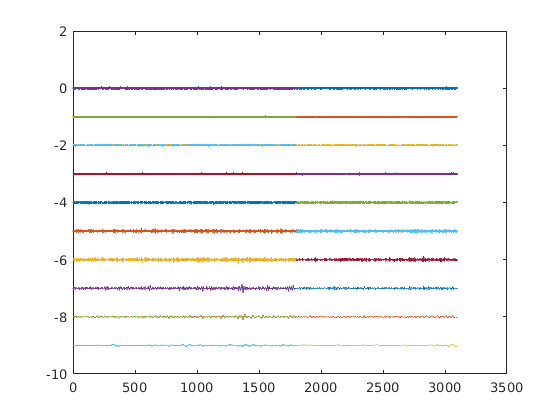

tspanFold = finResultsFold.sim_1(1:310000,1);
clf
for i =1:1:20
    if i==1
        plot(tspanFold, imf_eemd_fold(:,i))
    hold on
    end
    if i>1
        if i <=10
            plot(tspanFold, imf_eemd_fold(:,i)-1*(i-1))
        end
        if i >10
            idx = rem(i,11)+1;

            plot(tspan, imf_eemd(:,idx)-1*(rem(i,11)))
        end        
    end
end

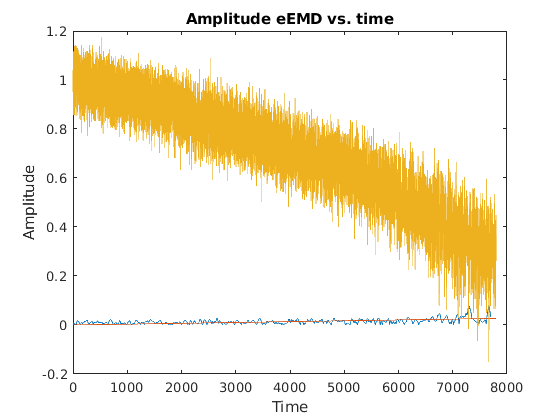

plot(df_fold(:,2), df_fold(:,3))

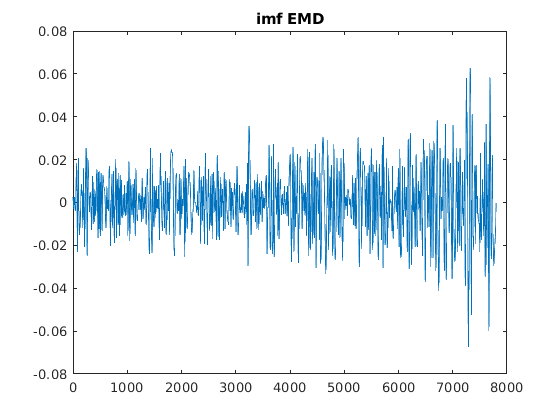

clf
plot(df_fold(:,2), imf(:,9))
title("imf EMD")

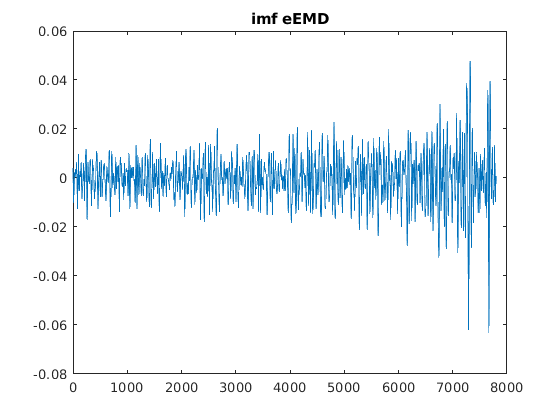

clf
plot(df_fold(:,2), imf_eemd(:,10))
title("imf eEMD")

[hs,f,t,imfinsf,imfinse] = hht(imf,100);
[hs_eemd,f_eemd,t,imfinsf_eemd,imfinse_eemd] = hht(imf_eemd,100);

%t = t(1:40000)

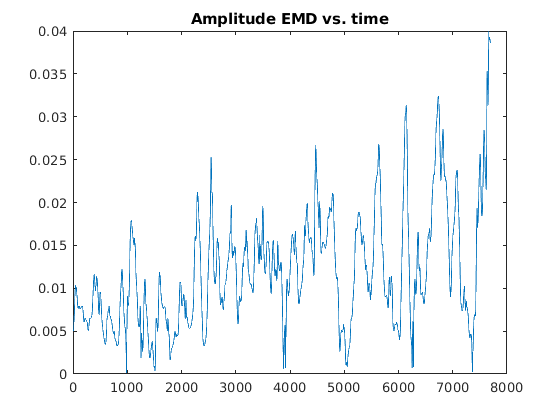

clf
plot(t(1000:770000,1), sqrt(imfinse(1000:770000,10)) )
title("Amplitude EMD vs. time")

%xlim([7000,8000])

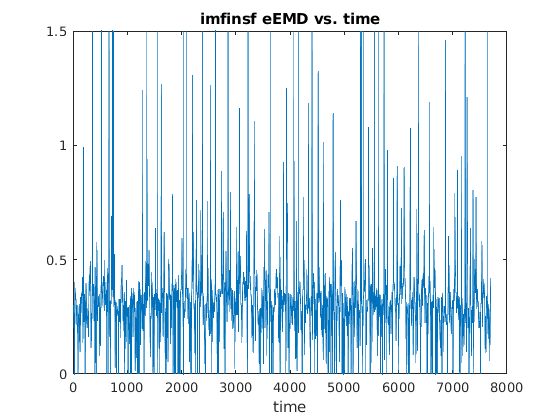

clf
plot(t(1000:770000,1), 2.*pi.*imfinsf_eemd(1000:770000,9))
title("imfinsf eEMD vs. time")
%xlim([350,450])
xlabel("time")
ylim([0,1.5])

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
b1 = t(1000:770000,1)\sqrt(imfinse_eemd(1000:770000,9))

b1 = 3.7377e-06

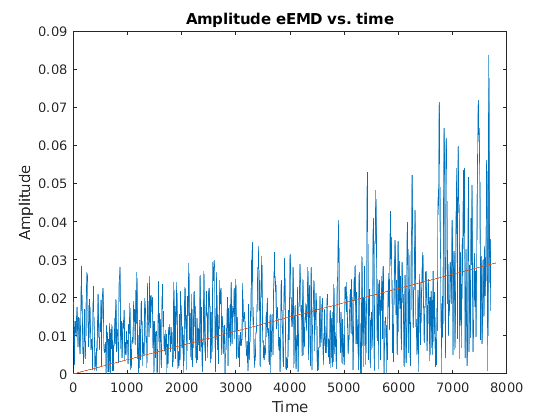

clf
plot(t(1000:770000,1), sqrt(imfinse_eemd(1000:770000,9)) )
hold on
plot(t, b1.*t)
title("Amplitude eEMD vs. time")
xlabel("Time")
ylabel("Amplitude")

%xlim([7700,7950])


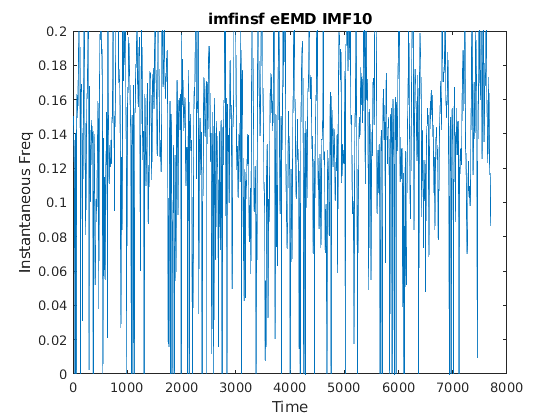

% IMF 10 has a very significant energy increase as 
% the bifurcation is approached
clf 
plot(t(1000:770000,1), 2.*pi.*imfinsf_eemd(1000:770000,10))
title("imfinsf eEMD IMF10")
xlabel("Time")
ylabel("Instantaneous Freq")
%xlim([7000,8500])
ylim([0,0.2])

clf 
imf_num = 10

imf_num = 10

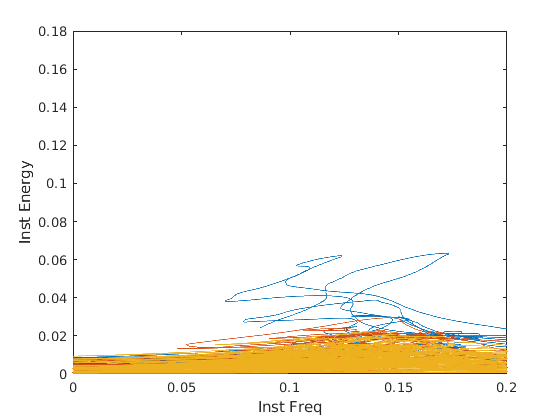

plot(2.*pi.*imfinsf_eemd(1000:770000,imf_num),sqrt(imfinse_eemd(1000:770000,imf_num)))
hold on
plot(2.*pi.*imfinsf_eemd(1000:670000,imf_num),sqrt(imfinse_eemd(1000:670000,imf_num)))
plot(2.*pi.*imfinsf_eemd(1000:470000,imf_num),sqrt(imfinse_eemd(1000:470000,imf_num)))

xlabel("Inst Freq")
ylabel("Inst Energy")
%xlim([0,0.05])
xlim([0,0.2])
ylim([0,0.18])

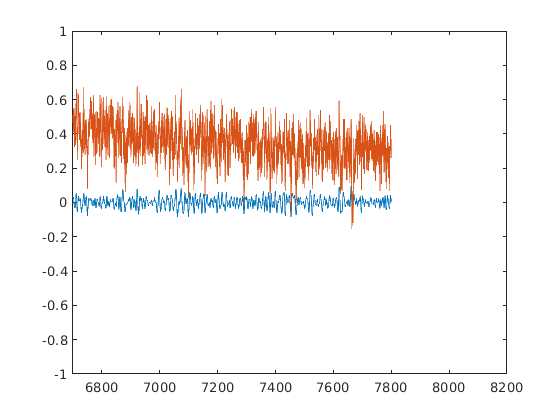

clf
plot(t, imf_eemd(:,8))
hold on
plot(t, df_fold(:,3))
xlim([6700,8200])
ylim([-1,1])

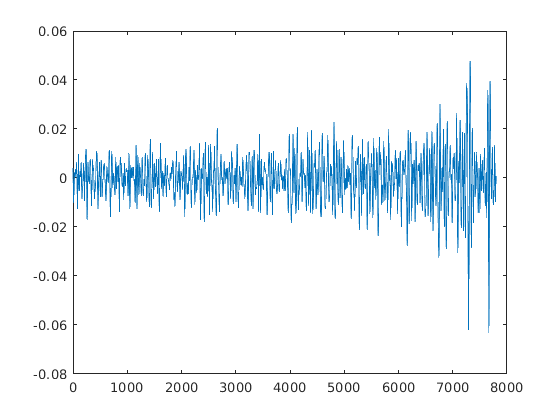

clf
plot(t, imf_eemd(:,10))

%xlim([0,450])

plot(t, imf_eemd(:,10))


[hs,f,t,imfinsf,imfinse] = hht(sum(imf(:,5:end),2),100);
%[hs_eemd,f_eemd,t,imfinsf_eemd,imfinse_eemd] = hht(imf_eemd,100);

clf
plot(t(10:770000,1), sqrt(imfinse(10:770000,1)))
b1 = t(1000:770000,1)\sqrt(imfinse(1000:770000,1))

b1 = 1.5687e-05

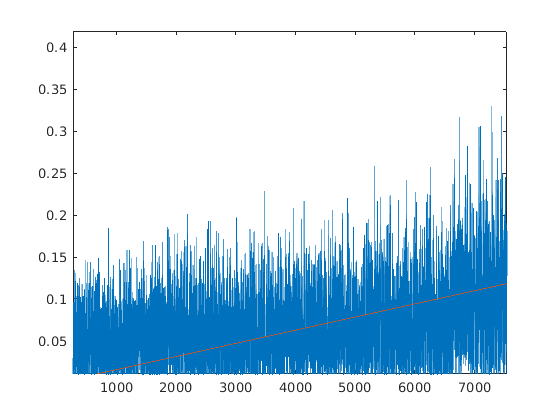

hold on
plot(t(1000:770000,1), b1.*t(1000:770000,1))

%ylim([0,10])

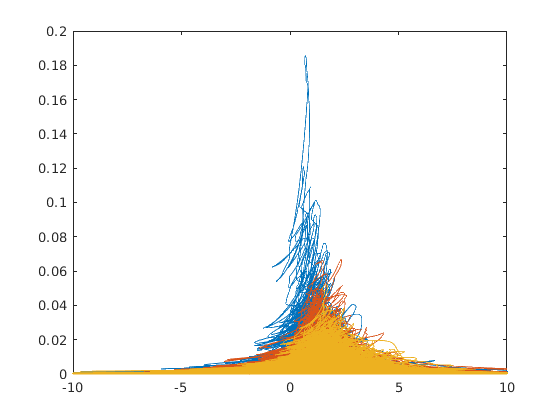

clf 
plot(2.*pi.*imfinsf(10:770000,1), imfinse(10:770000,1))%, 'Marker','.','LineStyle','none')
hold on
plot(2.*pi.*imfinsf(10:650000,1), imfinse(10:650000,1))
plot(2.*pi.*imfinsf(10:350000,1), imfinse(10:350000,1))
xlim([-10,10])